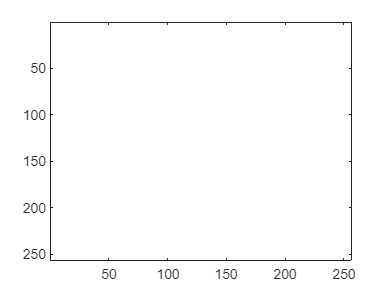

clear;

load("waves.mat");
ftwaves = fft2(waves);

imagesc(waves);

imagesc(abs(ftwaves)); %black :)

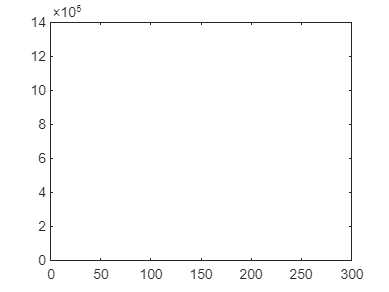

plot(abs(ftwaves))

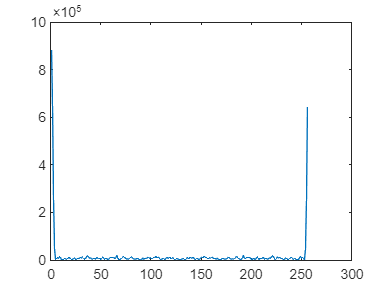

%plot(abs(ftwaves(1,:))- abs(ftwaves))
plot(abs(ftwaves(2,:)))



ftshitwaves = fftshift(ftwaves);
imagesc(abs(ftshitwaves))

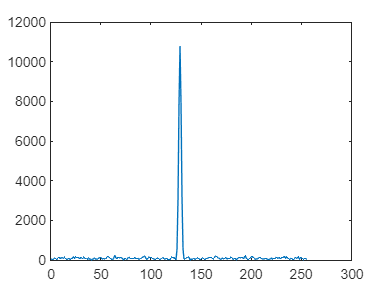

plot(abs(ftshitwaves(2,:)))

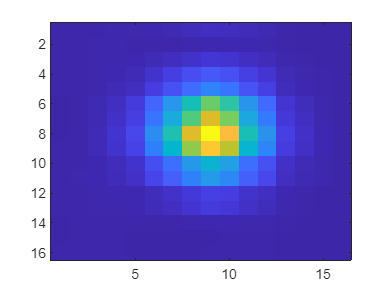


shortwaves = waves(1:16:256,1:16:256);
imagesc(abs(shortwaves));

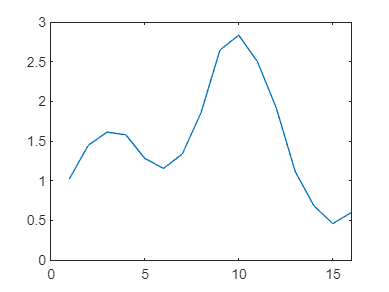

plot(abs(shortwaves(2,:)))


sus = ifft2(fftshift(fftshift(fft2(shortwaves))));
gus = ifft2(fft2(shortwaves)); % ^^ the same thing :) fftshift two times reveses the function
pus = fftshift(fftshift(shortwaves));
kus = shortwaves;
%sus = gus = pus = kus

imagesc(gus)

imagesc(sus)

%sus - gus = 0




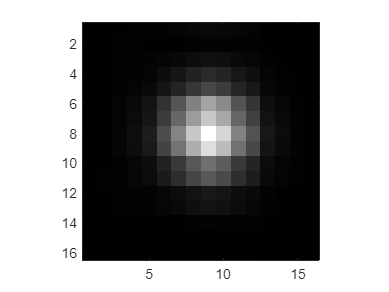



ORIGIM = imread('cameraman.tif');
ORIGIM = double(ORIGIM);
distance_map = zeros(16, 16);
for n  = 1:16
 for m = 1:16
    distance_map(n,m) = manhattan(n, m, 9, 9);
 end
end
axis image;
colormap gray;

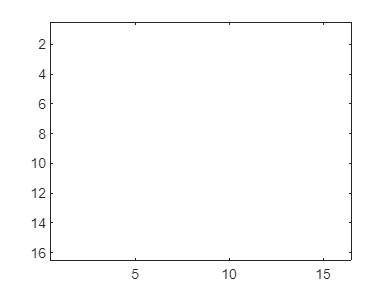

imagesc(distance_map);

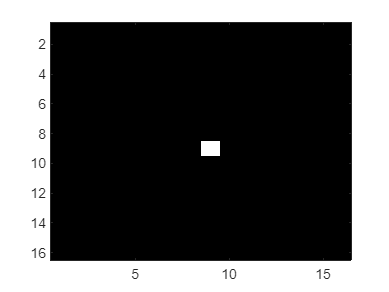

k = 0;
mask = (distance_map <= k);

% part 2
ftshortwaves0 = fftshift(fft2(shortwaves)) .* mask;
% rec0 = shortwaves * mask, shows the part of shortwaves which the mask lets through
rec0 = ifft2(fftshift(ftshortwaves0));

imagesc(ftshortwaves0); % shows the dot which the mask lets through

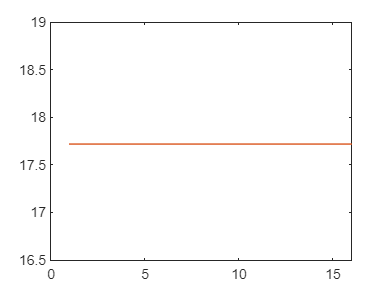

%imagesc(rec0)
plot(rec0)

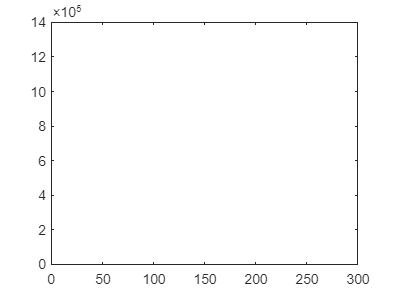

%imagesc(abs(rec0))

imagesc(shortwaves)

realG = abs(real(rec0))

realG =    17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.

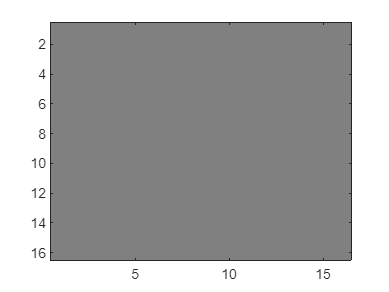

%realG = real(rec0);
imagesc(realG)


imagesc(abs(rec0))

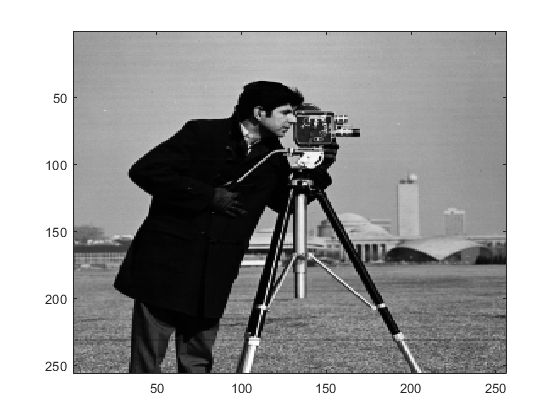

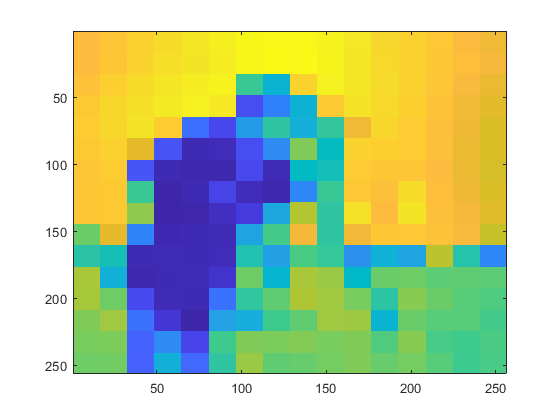

subimage = 	1.0e+04 *

   0.0019 + 0.0000i  -0.0033 - 0.0044i  -0.0008 + 0.0023i   0.0003 - 0.0002i  -0.0030 + 0.0011i   0.0028 - 0.0014i  -0.0000 + 0.0019i   0.0013 - 0.0021i   0.0033 + 0.0000i   0.0013 + 0.0021i  -0.0000 - 0.0019i   0.0028 + 0.0014i  -0.0030 - 0.0011i   0.0003 + 0.0002i  -0.0008 - 0.0023i  -0.0033 + 0.0044i
  -0.0025 - 0.0009i  -0.0021 + 0.0020i  -0.0023 + 0.0000i   0.0015 + 0.0033i  -0.0012 + 0.0032i   0.0002 + 0.0019i  -0.0009 + 0.0004i  -0.0018 - 0.0005i   0.0050 + 0.0087i  -0.0007 - 0.0005i  -0.0010 + 0.0022i  -0.0005 + 0.0013i   0.0008 + 0.0040i  -0.0026 - 0.0032i  -0.0018 - 0.0005i   0.0021 - 0.0000i
  -0.0008 - 0.0013i   0.0007 + 0.0023i  -0.0014 + 0.0030i   0.0000 - 0.0022i   0.0004 + 0.0008i   0.0045 + 0.0020i   0.0017 - 0.0002i  -0.0015 - 0.0012i  -0.0048 - 0.0009i   0.0005 - 0.0013i  -0.0008 + 0.0008i  -0.0022 - 0.0009i  -0.0026 - 0.0014i  -0.0039 + 0.0039i  -0.0016 + 0.0021i  -0.0011 + 0.0036i
   0.0014 + 0.0015i  -0.0029 + 0.0000i  -0.0029 + 0.0011i   0.

subimage = 	1.0e+04 *

   0.0001 + 0.0000i  -0.0091 - 0.0061i   0.0011 + 0.0009i   0.0020 - 0.0028i   0.0010 - 0.0035i   0.0014 + 0.0027i  -0.0027 + 0.0009i   0.0000 + 0.0026i  -0.0005 + 0.0000i   0.0000 - 0.0026i  -0.0027 - 0.0009i   0.0014 - 0.0027i   0.0010 + 0.0035i   0.0020 + 0.0028i   0.0011 - 0.0009i  -0.0091 + 0.0061i
  -0.0017 + 0.0033i  -0.0017 + 0.0010i   0.0025 + 0.0015i  -0.0018 - 0.0010i   0.0012 + 0.0011i   0.0001 + 0.0008i  -0.0015 + 0.0025i   0.0013 - 0.0013i  -0.0008 + 0.0103i  -0.0059 - 0.0004i  -0.0018 - 0.0006i  -0.0032 - 0.0028i   0.0013 - 0.0021i   0.0016 + 0.0033i  -0.0024 + 0.0029i   0.0018 + 0.0002i
   0.0029 - 0.0001i  -0.0021 - 0.0008i  -0.0009 + 0.0042i   0.0000 - 0.0026i  -0.0013 - 0.0052i  -0.0002 + 0.0011i   0.0039 - 0.0038i   0.0019 + 0.0024i   0.0007 - 0.0010i  -0.0041 + 0.0035i   0.0019 - 0.0004i  -0.0002 - 0.0022i  -0.0018 - 0.0032i  -0.0004 - 0.0013i  -0.0003 + 0.0007i  -0.0000 + 0.0017i
  -0.0015 - 0.0028i   0.0025 - 0.0033i  -0.0017 + 0.0005i  -0.

subimage = 	1.0e+04 *

   0.0032 + 0.0000i   0.0008 + 0.0006i   0.0030 - 0.0022i   0.0011 + 0.0005i  -0.0024 - 0.0014i  -0.0030 - 0.0002i   0.0016 + 0.0020i  -0.0018 + 0.0039i  -0.0020 + 0.0000i  -0.0018 - 0.0039i   0.0016 - 0.0020i  -0.0030 + 0.0002i  -0.0024 + 0.0014i   0.0011 - 0.0005i   0.0030 + 0.0022i   0.0008 - 0.0006i
   0.0022 - 0.0029i   0.0009 + 0.0005i  -0.0000 + 0.0000i   0.0011 - 0.0008i  -0.0013 - 0.0016i  -0.0049 + 0.0001i   0.0009 - 0.0006i   0.0027 - 0.0002i  -0.0043 + 0.0116i   0.0031 + 0.0010i  -0.0016 - 0.0015i   0.0012 + 0.0011i  -0.0004 - 0.0003i   0.0028 - 0.0001i   0.0010 - 0.0010i   0.0009 - 0.0030i
   0.0046 - 0.0015i  -0.0031 - 0.0009i  -0.0016 + 0.0022i  -0.0007 + 0.0011i   0.0009 + 0.0007i  -0.0000 + 0.0010i   0.0050 - 0.0054i  -0.0008 + 0.0017i  -0.0018 - 0.0075i  -0.0021 - 0.0007i  -0.0033 - 0.0016i   0.0008 + 0.0011i  -0.0028 + 0.0004i   0.0036 + 0.0010i  -0.0027 + 0.0001i   0.0006 - 0.0013i
  -0.0015 + 0.0031i  -0.0010 + 0.0010i  -0.0009 - 0.0014i  -0.

subimage = 	1.0e+04 *

   0.0005 + 0.0000i   0.0073 - 0.0034i   0.0007 + 0.0009i   0.0026 - 0.0023i   0.0024 + 0.0019i   0.0017 - 0.0037i  -0.0003 - 0.0047i  -0.0036 - 0.0032i  -0.0061 + 0.0000i  -0.0036 + 0.0032i  -0.0003 + 0.0047i   0.0017 + 0.0037i   0.0024 - 0.0019i   0.0026 + 0.0023i   0.0007 - 0.0009i   0.0073 + 0.0034i
  -0.0000 + 0.0044i  -0.0000 - 0.0013i  -0.0042 + 0.0023i  -0.0071 + 0.0055i  -0.0036 + 0.0017i  -0.0009 + 0.0002i   0.0011 - 0.0047i  -0.0010 - 0.0004i  -0.0053 + 0.0079i   0.0024 + 0.0007i  -0.0022 + 0.0016i   0.0019 + 0.0026i   0.0019 - 0.0036i   0.0017 - 0.0004i   0.0003 + 0.0027i   0.0038 + 0.0011i
   0.0026 + 0.0009i  -0.0012 + 0.0017i  -0.0012 - 0.0027i  -0.0019 - 0.0003i  -0.0017 - 0.0011i   0.0013 + 0.0001i   0.0009 - 0.0021i  -0.0013 + 0.0001i  -0.0023 - 0.0083i   0.0038 + 0.0011i   0.0016 - 0.0025i   0.0007 - 0.0038i  -0.0007 + 0.0024i  -0.0018 + 0.0015i  -0.0001 + 0.0034i   0.0013 + 0.0010i
  -0.0004 - 0.0011i   0.0035 - 0.0006i  -0.0028 + 0.0026i   0.

subimage = 	1.0e+04 *

   0.0015 + 0.0000i  -0.0046 + 0.0030i  -0.0012 - 0.0002i   0.0017 - 0.0026i  -0.0033 - 0.0020i  -0.0014 - 0.0038i  -0.0032 + 0.0036i  -0.0038 - 0.0022i  -0.0021 + 0.0000i  -0.0038 + 0.0022i  -0.0032 - 0.0036i  -0.0014 + 0.0038i  -0.0033 + 0.0020i   0.0017 + 0.0026i  -0.0012 + 0.0002i  -0.0046 - 0.0030i
  -0.0010 - 0.0022i   0.0023 + 0.0012i  -0.0012 + 0.0016i  -0.0009 - 0.0026i  -0.0023 - 0.0021i  -0.0028 - 0.0027i   0.0010 - 0.0056i  -0.0056 + 0.0001i   0.0010 + 0.0015i  -0.0015 + 0.0014i  -0.0016 + 0.0007i  -0.0041 - 0.0006i  -0.0020 + 0.0027i  -0.0030 - 0.0007i  -0.0014 - 0.0038i  -0.0008 - 0.0013i
  -0.0017 - 0.0025i  -0.0007 - 0.0012i   0.0002 - 0.0039i   0.0012 + 0.0007i  -0.0013 - 0.0001i   0.0009 - 0.0047i  -0.0015 - 0.0027i  -0.0027 - 0.0022i   0.0001 - 0.0013i  -0.0043 + 0.0007i  -0.0005 - 0.0002i   0.0015 - 0.0026i   0.0000 + 0.0012i   0.0011 - 0.0003i  -0.0028 + 0.0007i  -0.0020 - 0.0046i
   0.0002 + 0.0003i   0.0014 - 0.0025i  -0.0036 + 0.0011i   0.

subimage = 	1.0e+04 *

  -0.0002 + 0.0000i  -0.0019 + 0.0047i   0.0002 - 0.0060i   0.0028 - 0.0024i   0.0032 + 0.0030i  -0.0022 + 0.0014i  -0.0006 + 0.0000i  -0.0003 - 0.0043i  -0.0022 + 0.0000i  -0.0003 + 0.0043i  -0.0006 - 0.0000i  -0.0022 - 0.0014i   0.0032 - 0.0030i   0.0028 + 0.0024i   0.0002 + 0.0060i  -0.0019 - 0.0047i
  -0.0004 + 0.0015i  -0.0025 + 0.0010i  -0.0012 - 0.0003i  -0.0022 - 0.0004i  -0.0014 + 0.0012i   0.0004 + 0.0000i   0.0010 - 0.0024i  -0.0036 - 0.0000i   0.0029 + 0.0023i   0.0027 + 0.0016i   0.0003 + 0.0006i  -0.0012 + 0.0013i  -0.0004 + 0.0020i  -0.0012 + 0.0020i   0.0044 - 0.0019i  -0.0008 - 0.0009i
  -0.0013 + 0.0009i  -0.0000 + 0.0020i   0.0012 - 0.0023i  -0.0038 + 0.0016i  -0.0019 - 0.0011i   0.0027 + 0.0029i   0.0014 + 0.0025i   0.0012 - 0.0000i   0.0028 + 0.0007i   0.0003 + 0.0015i   0.0041 + 0.0030i  -0.0002 - 0.0012i  -0.0014 + 0.0003i   0.0022 - 0.0000i   0.0001 + 0.0007i  -0.0008 - 0.0014i
  -0.0005 + 0.0019i   0.0006 + 0.0009i   0.0005 - 0.0003i   0.

subimage = 	1.0e+04 *

   0.0047 + 0.0000i  -0.0011 - 0.0036i  -0.0009 + 0.0035i  -0.0029 + 0.0012i   0.0002 - 0.0019i  -0.0010 - 0.0002i  -0.0065 + 0.0029i   0.0014 - 0.0025i   0.0041 + 0.0000i   0.0014 + 0.0025i  -0.0065 - 0.0029i  -0.0010 + 0.0002i   0.0002 + 0.0019i  -0.0029 - 0.0012i  -0.0009 - 0.0035i  -0.0011 + 0.0036i
   0.0023 - 0.0002i   0.0008 + 0.0018i   0.0001 + 0.0030i  -0.0003 - 0.0022i  -0.0018 + 0.0023i  -0.0004 - 0.0011i  -0.0053 + 0.0020i  -0.0007 + 0.0006i   0.0079 - 0.0028i  -0.0003 - 0.0007i  -0.0016 + 0.0007i   0.0028 - 0.0016i   0.0012 - 0.0004i   0.0014 - 0.0036i  -0.0012 + 0.0020i   0.0007 - 0.0002i
  -0.0010 - 0.0010i  -0.0020 - 0.0008i   0.0011 + 0.0007i   0.0035 + 0.0003i  -0.0015 - 0.0016i  -0.0039 + 0.0000i   0.0025 + 0.0001i   0.0030 + 0.0021i  -0.0003 + 0.0012i  -0.0016 - 0.0014i   0.0027 - 0.0020i   0.0013 + 0.0019i  -0.0015 + 0.0005i   0.0014 - 0.0030i   0.0036 + 0.0034i   0.0032 - 0.0022i
  -0.0014 - 0.0004i  -0.0002 + 0.0027i   0.0005 + 0.0009i  -0.

subimage = 	1.0e+04 *

  -0.0015 + 0.0000i   0.0005 + 0.0004i  -0.0020 + 0.0001i  -0.0014 - 0.0003i  -0.0015 - 0.0012i   0.0001 - 0.0026i   0.0020 + 0.0007i  -0.0016 + 0.0029i  -0.0003 + 0.0000i  -0.0016 - 0.0029i   0.0020 - 0.0007i   0.0001 + 0.0026i  -0.0015 + 0.0012i  -0.0014 + 0.0003i  -0.0020 - 0.0001i   0.0005 - 0.0004i
   0.0007 + 0.0022i   0.0047 - 0.0011i  -0.0005 - 0.0004i  -0.0018 + 0.0017i  -0.0007 - 0.0035i   0.0016 + 0.0012i   0.0023 + 0.0004i   0.0008 - 0.0003i   0.0067 - 0.0018i   0.0006 - 0.0016i  -0.0013 + 0.0003i   0.0013 - 0.0003i  -0.0031 + 0.0035i  -0.0012 + 0.0047i  -0.0007 - 0.0027i   0.0003 + 0.0008i
  -0.0006 - 0.0005i   0.0018 - 0.0021i   0.0019 + 0.0030i  -0.0011 + 0.0006i  -0.0003 + 0.0032i   0.0010 - 0.0002i   0.0021 - 0.0011i   0.0063 + 0.0024i   0.0020 + 0.0028i  -0.0025 + 0.0030i   0.0005 - 0.0005i  -0.0004 - 0.0006i   0.0018 - 0.0015i  -0.0026 + 0.0016i  -0.0006 + 0.0015i   0.0007 - 0.0006i
   0.0003 + 0.0022i   0.0003 + 0.0024i  -0.0031 - 0.0029i   0.

subimage = 	1.0e+04 *

   0.0002 + 0.0000i   0.0033 - 0.0049i   0.0015 - 0.0027i   0.0006 - 0.0038i  -0.0005 + 0.0019i   0.0029 + 0.0015i  -0.0003 - 0.0009i   0.0004 - 0.0004i  -0.0048 + 0.0000i   0.0004 + 0.0004i  -0.0003 + 0.0009i   0.0029 - 0.0015i  -0.0005 - 0.0019i   0.0006 + 0.0038i   0.0015 + 0.0027i   0.0033 + 0.0049i
  -0.0001 - 0.0024i   0.0013 - 0.0032i   0.0027 - 0.0020i  -0.0031 - 0.0026i  -0.0020 + 0.0003i  -0.0003 - 0.0008i   0.0021 - 0.0025i   0.0035 - 0.0021i   0.0093 - 0.0027i   0.0018 + 0.0024i  -0.0008 + 0.0011i  -0.0023 - 0.0015i  -0.0008 + 0.0029i   0.0033 + 0.0018i   0.0024 - 0.0036i   0.0032 + 0.0011i
   0.0001 - 0.0014i   0.0002 - 0.0023i  -0.0009 - 0.0062i   0.0024 - 0.0041i   0.0014 + 0.0010i   0.0012 - 0.0024i  -0.0005 + 0.0038i   0.0022 - 0.0027i  -0.0031 + 0.0047i  -0.0023 - 0.0020i  -0.0010 + 0.0014i   0.0004 - 0.0006i  -0.0028 + 0.0012i   0.0021 + 0.0008i   0.0038 - 0.0029i  -0.0001 + 0.0017i
  -0.0002 - 0.0010i  -0.0004 + 0.0002i   0.0004 - 0.0026i  -0.

subimage = 	1.0e+04 *

   0.0006 + 0.0000i  -0.0004 - 0.0022i  -0.0038 + 0.0032i   0.0021 + 0.0003i   0.0015 + 0.0017i  -0.0008 - 0.0027i  -0.0008 + 0.0004i  -0.0012 + 0.0012i  -0.0016 + 0.0000i  -0.0012 - 0.0012i  -0.0008 - 0.0004i  -0.0008 + 0.0027i   0.0015 - 0.0017i   0.0021 - 0.0003i  -0.0038 - 0.0032i  -0.0004 + 0.0022i
   0.0003 + 0.0015i   0.0011 - 0.0035i  -0.0004 + 0.0028i   0.0022 - 0.0018i   0.0009 - 0.0016i   0.0019 + 0.0004i   0.0009 - 0.0015i  -0.0003 + 0.0023i   0.0083 - 0.0008i  -0.0004 - 0.0001i  -0.0003 - 0.0015i   0.0020 - 0.0005i   0.0026 - 0.0009i  -0.0018 + 0.0022i   0.0020 - 0.0029i   0.0056 - 0.0002i
  -0.0015 - 0.0011i  -0.0004 - 0.0000i  -0.0034 - 0.0012i  -0.0004 - 0.0009i   0.0031 - 0.0001i   0.0023 - 0.0007i   0.0011 - 0.0002i  -0.0024 + 0.0004i  -0.0017 + 0.0065i   0.0030 + 0.0018i   0.0017 + 0.0004i   0.0010 - 0.0014i   0.0036 - 0.0009i  -0.0005 - 0.0007i  -0.0005 + 0.0031i   0.0009 - 0.0014i
  -0.0017 - 0.0027i  -0.0013 - 0.0041i   0.0003 + 0.0020i   0.

subimage = 	1.0e+04 *

  -0.0066 + 0.0000i  -0.0011 - 0.0013i  -0.0028 + 0.0008i  -0.0026 - 0.0001i  -0.0027 - 0.0001i   0.0027 + 0.0000i   0.0008 + 0.0030i  -0.0018 - 0.0000i  -0.0040 + 0.0000i  -0.0018 + 0.0000i   0.0008 - 0.0030i   0.0027 - 0.0000i  -0.0027 + 0.0001i  -0.0026 + 0.0001i  -0.0028 - 0.0008i  -0.0011 + 0.0013i
  -0.0014 + 0.0022i  -0.0001 - 0.0003i  -0.0034 + 0.0014i  -0.0022 + 0.0020i   0.0021 + 0.0005i   0.0032 - 0.0016i   0.0044 + 0.0006i   0.0006 + 0.0020i   0.0095 + 0.0019i  -0.0029 - 0.0033i   0.0001 - 0.0031i   0.0001 - 0.0001i  -0.0001 - 0.0006i   0.0028 - 0.0003i   0.0015 + 0.0018i   0.0002 - 0.0013i
  -0.0026 + 0.0035i  -0.0032 + 0.0004i  -0.0060 + 0.0015i  -0.0003 + 0.0034i  -0.0053 + 0.0002i   0.0048 - 0.0044i   0.0011 - 0.0022i   0.0018 + 0.0002i  -0.0035 + 0.0006i   0.0038 + 0.0005i  -0.0000 - 0.0007i  -0.0009 + 0.0017i  -0.0024 + 0.0045i   0.0022 - 0.0019i  -0.0014 - 0.0007i   0.0015 + 0.0012i
   0.0030 + 0.0008i  -0.0015 - 0.0028i   0.0013 - 0.0011i  -0.

subimage = 	1.0e+04 *

   0.0014 + 0.0000i   0.0004 - 0.0016i   0.0005 + 0.0018i   0.0005 + 0.0026i   0.0010 - 0.0004i  -0.0025 + 0.0030i   0.0003 + 0.0002i   0.0009 + 0.0020i  -0.0002 + 0.0000i   0.0009 - 0.0020i   0.0003 - 0.0002i  -0.0025 - 0.0030i   0.0010 + 0.0004i   0.0005 - 0.0026i   0.0005 - 0.0018i   0.0004 + 0.0016i
  -0.0043 + 0.0010i   0.0027 - 0.0024i   0.0004 - 0.0005i   0.0020 + 0.0003i   0.0005 + 0.0013i  -0.0004 - 0.0017i  -0.0028 + 0.0003i   0.0070 + 0.0009i   0.0002 + 0.0048i  -0.0014 - 0.0080i  -0.0013 - 0.0010i  -0.0022 + 0.0012i  -0.0029 + 0.0001i  -0.0019 + 0.0001i   0.0001 + 0.0009i  -0.0010 + 0.0007i
  -0.0006 + 0.0007i   0.0003 - 0.0003i  -0.0012 + 0.0012i  -0.0013 - 0.0012i   0.0009 - 0.0015i   0.0030 + 0.0014i   0.0007 + 0.0010i   0.0026 - 0.0046i   0.0018 + 0.0015i   0.0021 + 0.0006i   0.0019 - 0.0021i  -0.0036 - 0.0038i   0.0012 + 0.0007i   0.0003 + 0.0034i  -0.0004 - 0.0006i  -0.0042 + 0.0012i
  -0.0011 + 0.0019i   0.0037 - 0.0020i  -0.0033 - 0.0002i  -0.

subimage = 	1.0e+04 *

   0.0028 + 0.0000i  -0.0008 - 0.0003i   0.0019 - 0.0003i  -0.0026 - 0.0011i   0.0002 + 0.0000i   0.0001 - 0.0003i  -0.0017 + 0.0039i   0.0009 - 0.0031i  -0.0020 + 0.0000i   0.0009 + 0.0031i  -0.0017 - 0.0039i   0.0001 + 0.0003i   0.0002 + 0.0000i  -0.0026 + 0.0011i   0.0019 + 0.0003i  -0.0008 + 0.0003i
   0.0014 - 0.0013i   0.0034 - 0.0013i  -0.0012 - 0.0025i   0.0030 - 0.0003i   0.0011 + 0.0059i  -0.0004 - 0.0006i   0.0016 - 0.0000i  -0.0016 + 0.0011i  -0.0035 + 0.0076i   0.0006 - 0.0025i   0.0028 - 0.0020i   0.0030 - 0.0005i  -0.0026 + 0.0045i   0.0010 - 0.0016i  -0.0015 + 0.0017i   0.0068 + 0.0011i
  -0.0034 - 0.0027i   0.0023 + 0.0019i  -0.0003 + 0.0002i  -0.0039 - 0.0033i  -0.0007 + 0.0031i  -0.0001 - 0.0013i   0.0003 - 0.0009i   0.0050 - 0.0027i  -0.0047 - 0.0010i  -0.0014 + 0.0009i  -0.0001 + 0.0011i   0.0019 + 0.0007i  -0.0026 + 0.0003i  -0.0008 - 0.0024i   0.0011 - 0.0040i   0.0005 + 0.0022i
   0.0009 - 0.0003i  -0.0040 + 0.0008i  -0.0001 + 0.0007i  -0.

subimage = 	1.0e+04 *

  -0.0028 + 0.0000i  -0.0013 - 0.0014i   0.0034 + 0.0004i   0.0012 - 0.0100i  -0.0017 + 0.0011i  -0.0006 + 0.0035i   0.0002 + 0.0018i  -0.0025 - 0.0022i  -0.0042 + 0.0000i  -0.0025 + 0.0022i   0.0002 - 0.0018i  -0.0006 - 0.0035i  -0.0017 - 0.0011i   0.0012 + 0.0100i   0.0034 - 0.0004i  -0.0013 + 0.0014i
   0.0027 - 0.0004i   0.0009 + 0.0004i  -0.0012 + 0.0011i  -0.0006 - 0.0025i  -0.0019 - 0.0017i   0.0006 + 0.0029i  -0.0010 - 0.0008i  -0.0012 + 0.0004i  -0.0045 - 0.0002i   0.0045 + 0.0021i  -0.0031 + 0.0034i  -0.0036 - 0.0009i  -0.0007 - 0.0063i   0.0015 - 0.0035i  -0.0007 - 0.0013i   0.0003 + 0.0022i
  -0.0013 + 0.0012i   0.0002 - 0.0064i   0.0013 + 0.0007i  -0.0034 - 0.0011i   0.0022 - 0.0019i  -0.0040 - 0.0035i   0.0053 + 0.0015i   0.0005 + 0.0053i  -0.0063 + 0.0001i   0.0015 - 0.0018i  -0.0026 - 0.0022i  -0.0026 - 0.0014i   0.0008 + 0.0028i   0.0034 + 0.0001i   0.0014 + 0.0019i  -0.0010 + 0.0002i
   0.0025 + 0.0009i   0.0017 + 0.0028i   0.0022 - 0.0015i  -0.

subimage = 	1.0e+04 *

   0.0001 + 0.0000i   0.0002 + 0.0004i  -0.0016 - 0.0015i   0.0019 + 0.0011i   0.0015 + 0.0008i   0.0003 - 0.0002i  -0.0038 - 0.0039i   0.0020 + 0.0023i  -0.0043 + 0.0000i   0.0020 - 0.0023i  -0.0038 + 0.0039i   0.0003 + 0.0002i   0.0015 - 0.0008i   0.0019 - 0.0011i  -0.0016 + 0.0015i   0.0002 - 0.0004i
   0.0034 + 0.0005i   0.0020 + 0.0009i  -0.0025 + 0.0006i   0.0031 - 0.0034i   0.0021 - 0.0021i  -0.0010 + 0.0040i  -0.0000 + 0.0015i   0.0030 - 0.0038i  -0.0110 - 0.0021i   0.0055 - 0.0025i   0.0009 + 0.0009i  -0.0002 + 0.0004i   0.0013 + 0.0026i  -0.0001 - 0.0004i  -0.0053 + 0.0021i  -0.0022 + 0.0030i
   0.0001 - 0.0004i  -0.0029 - 0.0015i   0.0017 + 0.0007i  -0.0006 + 0.0015i   0.0016 - 0.0020i   0.0015 + 0.0006i  -0.0001 - 0.0007i  -0.0011 - 0.0023i  -0.0001 - 0.0005i  -0.0024 - 0.0003i   0.0002 - 0.0024i   0.0015 + 0.0003i  -0.0014 - 0.0026i  -0.0003 - 0.0025i   0.0016 + 0.0034i   0.0012 - 0.0051i
   0.0024 + 0.0004i   0.0026 - 0.0014i  -0.0016 + 0.0016i  -0.

subimage = 	1.0e+04 *

   0.0053 + 0.0000i   0.0011 + 0.0020i  -0.0020 + 0.0000i   0.0008 - 0.0015i   0.0025 + 0.0018i   0.0005 - 0.0003i  -0.0032 - 0.0046i  -0.0012 - 0.0012i  -0.0007 + 0.0000i  -0.0012 + 0.0012i  -0.0032 + 0.0046i   0.0005 + 0.0003i   0.0025 - 0.0018i   0.0008 + 0.0015i  -0.0020 - 0.0000i   0.0011 - 0.0020i
  -0.0064 - 0.0021i  -0.0026 - 0.0008i   0.0007 - 0.0053i   0.0003 + 0.0015i  -0.0029 - 0.0063i   0.0044 - 0.0014i  -0.0017 + 0.0011i   0.0011 + 0.0018i  -0.0116 - 0.0007i   0.0013 + 0.0025i   0.0003 - 0.0019i  -0.0017 - 0.0038i  -0.0026 - 0.0016i   0.0065 + 0.0004i  -0.0010 - 0.0074i   0.0014 - 0.0043i
   0.0016 + 0.0003i  -0.0010 + 0.0007i   0.0005 - 0.0005i  -0.0002 - 0.0011i  -0.0005 + 0.0016i  -0.0028 - 0.0006i   0.0014 - 0.0022i  -0.0010 - 0.0005i  -0.0006 + 0.0055i  -0.0050 - 0.0029i   0.0007 - 0.0036i   0.0009 - 0.0036i   0.0030 + 0.0009i   0.0002 - 0.0029i   0.0027 - 0.0000i  -0.0024 + 0.0007i
  -0.0027 - 0.0017i   0.0011 - 0.0016i  -0.0033 - 0.0003i   0.

subimage = 	1.0e+04 *

  -0.0009 + 0.0000i   0.0033 + 0.0034i   0.0001 + 0.0019i   0.0035 + 0.0013i   0.0012 + 0.0037i  -0.0012 - 0.0008i   0.0027 - 0.0009i   0.0040 + 0.0005i  -0.0071 + 0.0000i   0.0040 - 0.0005i   0.0027 + 0.0009i  -0.0012 + 0.0008i   0.0012 - 0.0037i   0.0035 - 0.0013i   0.0001 - 0.0019i   0.0033 - 0.0034i
   0.0001 + 0.0023i   0.0013 + 0.0014i   0.0003 + 0.0003i  -0.0015 + 0.0005i  -0.0026 + 0.0003i   0.0049 - 0.0026i   0.0005 + 0.0012i   0.0010 + 0.0041i  -0.0024 + 0.0016i  -0.0016 - 0.0041i  -0.0020 + 0.0000i  -0.0026 + 0.0012i   0.0003 + 0.0023i  -0.0009 - 0.0013i   0.0010 + 0.0006i   0.0023 + 0.0005i
  -0.0015 - 0.0008i   0.0010 - 0.0017i   0.0021 + 0.0008i   0.0034 + 0.0015i   0.0009 + 0.0034i  -0.0008 - 0.0014i  -0.0002 - 0.0047i  -0.0010 - 0.0003i   0.0035 - 0.0036i  -0.0011 - 0.0031i  -0.0012 + 0.0013i  -0.0017 - 0.0024i  -0.0018 + 0.0013i   0.0005 - 0.0026i  -0.0007 - 0.0019i   0.0039 - 0.0015i
   0.0012 - 0.0016i   0.0014 + 0.0001i   0.0013 - 0.0007i   0.

subimage = 	1.0e+04 *

  -0.0008 + 0.0000i   0.0001 + 0.0002i  -0.0017 - 0.0005i   0.0009 + 0.0039i  -0.0024 + 0.0006i   0.0006 - 0.0019i  -0.0005 - 0.0007i   0.0040 - 0.0004i  -0.0076 + 0.0000i   0.0040 + 0.0004i  -0.0005 + 0.0007i   0.0006 + 0.0019i  -0.0024 - 0.0006i   0.0009 - 0.0039i  -0.0017 + 0.0005i   0.0001 - 0.0002i
  -0.0016 + 0.0008i   0.0001 + 0.0011i  -0.0018 - 0.0041i   0.0004 - 0.0037i   0.0011 - 0.0021i  -0.0015 + 0.0002i   0.0001 - 0.0013i   0.0040 + 0.0037i  -0.0104 + 0.0041i   0.0011 - 0.0024i   0.0007 + 0.0023i   0.0031 - 0.0013i  -0.0013 - 0.0025i  -0.0004 - 0.0034i   0.0020 + 0.0033i  -0.0012 + 0.0046i
  -0.0022 + 0.0030i  -0.0012 + 0.0016i   0.0038 + 0.0038i   0.0021 - 0.0002i   0.0010 - 0.0023i  -0.0006 - 0.0020i  -0.0008 + 0.0005i   0.0015 - 0.0016i  -0.0019 + 0.0025i   0.0004 - 0.0015i  -0.0019 + 0.0027i  -0.0002 - 0.0013i  -0.0024 - 0.0014i  -0.0022 - 0.0013i   0.0008 + 0.0001i  -0.0018 - 0.0008i
   0.0001 - 0.0004i  -0.0001 + 0.0013i  -0.0026 + 0.0001i  -0.

subimage = 	1.0e+04 *

  -0.0062 + 0.0000i   0.0019 - 0.0033i   0.0016 + 0.0021i  -0.0004 - 0.0005i   0.0030 - 0.0006i   0.0011 + 0.0020i  -0.0006 + 0.0007i   0.0019 + 0.0024i  -0.0074 + 0.0000i   0.0019 - 0.0024i  -0.0006 - 0.0007i   0.0011 - 0.0020i   0.0030 + 0.0006i  -0.0004 + 0.0005i   0.0016 - 0.0021i   0.0019 + 0.0033i
  -0.0009 + 0.0011i  -0.0007 + 0.0028i  -0.0008 - 0.0005i   0.0004 - 0.0018i   0.0005 + 0.0017i  -0.0001 + 0.0022i   0.0017 + 0.0010i   0.0013 - 0.0006i  -0.0074 + 0.0094i   0.0019 + 0.0014i  -0.0024 + 0.0025i   0.0026 + 0.0001i  -0.0038 + 0.0042i   0.0010 + 0.0033i   0.0001 + 0.0024i   0.0019 + 0.0002i
  -0.0017 + 0.0021i   0.0013 + 0.0000i  -0.0019 + 0.0001i  -0.0017 + 0.0044i  -0.0001 + 0.0026i  -0.0001 + 0.0018i  -0.0010 - 0.0008i  -0.0001 + 0.0050i  -0.0008 + 0.0025i  -0.0009 - 0.0008i  -0.0035 + 0.0029i   0.0024 - 0.0015i   0.0004 - 0.0027i  -0.0012 - 0.0026i   0.0012 - 0.0004i  -0.0027 - 0.0025i
   0.0013 + 0.0012i   0.0001 + 0.0011i  -0.0016 - 0.0017i  -0.

subimage = 	1.0e+04 *

   0.0051 + 0.0000i  -0.0019 + 0.0021i   0.0003 - 0.0025i  -0.0020 - 0.0010i  -0.0038 + 0.0003i   0.0007 - 0.0029i  -0.0013 - 0.0011i   0.0015 + 0.0015i  -0.0051 + 0.0000i   0.0015 - 0.0015i  -0.0013 + 0.0011i   0.0007 + 0.0029i  -0.0038 - 0.0003i  -0.0020 + 0.0010i   0.0003 + 0.0025i  -0.0019 - 0.0021i
  -0.0036 + 0.0025i   0.0006 - 0.0016i   0.0020 - 0.0016i  -0.0036 - 0.0012i  -0.0020 - 0.0021i   0.0030 - 0.0011i  -0.0022 + 0.0007i   0.0005 + 0.0004i  -0.0043 + 0.0025i   0.0019 + 0.0013i   0.0016 - 0.0023i   0.0010 + 0.0005i   0.0033 + 0.0007i  -0.0016 + 0.0010i   0.0000 - 0.0018i   0.0006 - 0.0011i
  -0.0017 - 0.0002i   0.0037 + 0.0006i   0.0030 - 0.0033i   0.0015 + 0.0002i  -0.0019 - 0.0001i  -0.0001 + 0.0007i   0.0033 + 0.0014i  -0.0012 - 0.0046i  -0.0028 + 0.0015i  -0.0027 + 0.0006i   0.0011 + 0.0007i   0.0026 - 0.0045i   0.0002 - 0.0007i   0.0004 - 0.0042i   0.0024 - 0.0010i  -0.0002 + 0.0015i
  -0.0052 - 0.0006i  -0.0009 + 0.0013i  -0.0001 - 0.0004i   0.

subimage = 	1.0e+04 *

   0.0038 + 0.0000i  -0.0011 + 0.0021i  -0.0016 - 0.0018i  -0.0012 - 0.0018i  -0.0008 - 0.0008i  -0.0014 + 0.0021i   0.0004 - 0.0022i  -0.0027 - 0.0029i   0.0034 + 0.0000i  -0.0027 + 0.0029i   0.0004 + 0.0022i  -0.0014 - 0.0021i  -0.0008 + 0.0008i  -0.0012 + 0.0018i  -0.0016 + 0.0018i  -0.0011 - 0.0021i
  -0.0001 + 0.0040i  -0.0022 - 0.0019i  -0.0004 + 0.0024i  -0.0034 + 0.0019i  -0.0016 - 0.0012i  -0.0041 + 0.0037i  -0.0006 - 0.0057i   0.0019 + 0.0016i   0.0008 + 0.0051i  -0.0002 + 0.0038i   0.0001 + 0.0031i   0.0006 - 0.0010i   0.0020 + 0.0014i   0.0010 + 0.0024i  -0.0008 - 0.0010i  -0.0005 + 0.0003i
   0.0009 - 0.0007i  -0.0019 - 0.0008i   0.0005 - 0.0006i  -0.0021 - 0.0004i   0.0003 - 0.0022i  -0.0033 + 0.0018i   0.0026 + 0.0024i  -0.0016 - 0.0034i  -0.0030 + 0.0032i  -0.0001 + 0.0006i  -0.0005 - 0.0008i   0.0022 + 0.0004i   0.0041 + 0.0012i   0.0006 - 0.0000i  -0.0029 - 0.0003i   0.0043 - 0.0032i
  -0.0008 + 0.0020i  -0.0025 + 0.0012i  -0.0019 - 0.0005i   0.

subimage = 	1.0e+04 *

   0.0026 + 0.0000i   0.0028 + 0.0001i   0.0008 - 0.0055i   0.0036 + 0.0001i   0.0010 + 0.0004i  -0.0009 - 0.0021i  -0.0020 + 0.0021i   0.0033 - 0.0005i   0.0042 + 0.0000i   0.0033 + 0.0005i  -0.0020 - 0.0021i  -0.0009 + 0.0021i   0.0010 - 0.0004i   0.0036 - 0.0001i   0.0008 + 0.0055i   0.0028 - 0.0001i
  -0.0007 - 0.0031i   0.0014 + 0.0039i  -0.0009 - 0.0006i  -0.0019 + 0.0015i  -0.0033 - 0.0003i   0.0007 + 0.0008i  -0.0008 - 0.0009i   0.0007 + 0.0001i   0.0058 + 0.0054i   0.0024 + 0.0038i   0.0034 - 0.0021i  -0.0018 + 0.0004i  -0.0024 - 0.0012i   0.0003 - 0.0004i   0.0004 + 0.0016i  -0.0032 + 0.0031i
   0.0006 + 0.0028i   0.0009 - 0.0034i   0.0018 - 0.0016i   0.0021 - 0.0016i   0.0014 + 0.0003i   0.0007 + 0.0015i  -0.0026 - 0.0015i  -0.0015 + 0.0003i  -0.0066 + 0.0020i   0.0027 + 0.0032i   0.0026 - 0.0010i  -0.0003 + 0.0011i  -0.0005 - 0.0001i   0.0020 - 0.0035i   0.0013 + 0.0026i  -0.0023 - 0.0000i
  -0.0004 + 0.0004i  -0.0019 - 0.0007i   0.0003 - 0.0018i   0.

subimage = 	1.0e+04 *

   0.0027 + 0.0000i  -0.0021 + 0.0012i  -0.0023 + 0.0005i   0.0015 + 0.0038i  -0.0002 - 0.0003i  -0.0020 - 0.0002i   0.0007 + 0.0033i  -0.0006 - 0.0004i   0.0041 + 0.0000i  -0.0006 + 0.0004i   0.0007 - 0.0033i  -0.0020 + 0.0002i  -0.0002 + 0.0003i   0.0015 - 0.0038i  -0.0023 - 0.0005i  -0.0021 - 0.0012i
   0.0024 + 0.0006i   0.0016 + 0.0036i  -0.0031 - 0.0004i   0.0012 + 0.0001i   0.0018 + 0.0021i   0.0035 + 0.0007i   0.0006 - 0.0041i   0.0007 + 0.0013i   0.0081 + 0.0077i  -0.0045 - 0.0027i   0.0054 - 0.0019i   0.0004 - 0.0028i  -0.0024 - 0.0021i   0.0017 - 0.0013i  -0.0014 + 0.0032i  -0.0014 - 0.0011i
   0.0020 - 0.0025i  -0.0019 + 0.0021i   0.0000 - 0.0029i   0.0001 + 0.0013i   0.0007 + 0.0013i  -0.0036 - 0.0008i   0.0014 - 0.0011i  -0.0012 + 0.0019i  -0.0069 - 0.0019i   0.0015 + 0.0012i   0.0004 - 0.0036i  -0.0031 + 0.0015i   0.0001 - 0.0006i  -0.0008 + 0.0010i  -0.0014 - 0.0001i  -0.0011 + 0.0013i
  -0.0024 - 0.0006i   0.0005 - 0.0008i  -0.0043 + 0.0002i  -0.

subimage = 	1.0e+04 *

   0.0010 + 0.0000i  -0.0036 + 0.0039i  -0.0002 - 0.0015i   0.0049 - 0.0015i   0.0010 + 0.0008i  -0.0004 + 0.0014i  -0.0004 + 0.0003i   0.0004 - 0.0004i   0.0038 + 0.0000i   0.0004 + 0.0004i  -0.0004 - 0.0003i  -0.0004 - 0.0014i   0.0010 - 0.0008i   0.0049 + 0.0015i  -0.0002 + 0.0015i  -0.0036 - 0.0039i
  -0.0007 - 0.0027i   0.0028 + 0.0003i  -0.0005 + 0.0007i   0.0019 - 0.0006i   0.0018 + 0.0013i  -0.0001 - 0.0018i   0.0028 - 0.0009i  -0.0005 + 0.0014i   0.0086 + 0.0062i  -0.0004 - 0.0015i   0.0000 - 0.0018i   0.0001 - 0.0002i  -0.0021 + 0.0011i   0.0014 - 0.0009i   0.0009 - 0.0020i   0.0010 - 0.0024i
  -0.0029 - 0.0010i   0.0014 - 0.0014i  -0.0004 + 0.0019i   0.0007 + 0.0016i   0.0008 + 0.0016i  -0.0014 + 0.0033i  -0.0024 + 0.0039i   0.0028 - 0.0013i  -0.0034 - 0.0035i  -0.0017 + 0.0000i   0.0027 - 0.0035i   0.0021 - 0.0034i   0.0022 + 0.0009i  -0.0006 - 0.0013i  -0.0019 - 0.0026i   0.0000 + 0.0018i
   0.0008 + 0.0007i   0.0020 - 0.0033i   0.0004 + 0.0021i   0.

subimage = 	1.0e+04 *

   0.0008 + 0.0000i  -0.0002 - 0.0006i   0.0002 - 0.0036i   0.0021 - 0.0000i  -0.0003 + 0.0035i   0.0025 + 0.0007i  -0.0002 + 0.0010i   0.0000 - 0.0011i   0.0022 + 0.0000i   0.0000 + 0.0011i  -0.0002 - 0.0010i   0.0025 - 0.0007i  -0.0003 - 0.0035i   0.0021 + 0.0000i   0.0002 + 0.0036i  -0.0002 + 0.0006i
  -0.0005 - 0.0010i  -0.0026 + 0.0011i  -0.0016 + 0.0027i   0.0004 + 0.0022i  -0.0005 + 0.0007i   0.0019 - 0.0004i   0.0001 + 0.0023i  -0.0007 + 0.0018i   0.0057 + 0.0076i  -0.0005 - 0.0000i   0.0004 + 0.0002i   0.0014 + 0.0028i  -0.0005 + 0.0005i  -0.0005 - 0.0010i   0.0020 + 0.0003i   0.0012 + 0.0014i
  -0.0000 - 0.0001i  -0.0001 - 0.0041i  -0.0028 - 0.0001i   0.0005 + 0.0012i  -0.0007 - 0.0023i  -0.0027 + 0.0008i  -0.0030 - 0.0009i   0.0002 - 0.0004i  -0.0029 - 0.0026i   0.0007 + 0.0026i   0.0018 + 0.0022i  -0.0025 - 0.0013i   0.0010 + 0.0021i   0.0004 - 0.0008i   0.0010 - 0.0008i  -0.0002 - 0.0016i
   0.0009 - 0.0022i  -0.0021 - 0.0020i   0.0022 + 0.0020i   0.

subimage = 	1.0e+04 *

  -0.0002 + 0.0000i  -0.0027 + 0.0007i  -0.0002 - 0.0000i   0.0000 - 0.0041i   0.0026 + 0.0002i  -0.0040 + 0.0007i   0.0004 - 0.0022i   0.0018 - 0.0045i  -0.0054 + 0.0000i   0.0018 + 0.0045i   0.0004 + 0.0022i  -0.0040 - 0.0007i   0.0026 - 0.0002i   0.0000 + 0.0041i  -0.0002 + 0.0000i  -0.0027 - 0.0007i
  -0.0005 - 0.0039i  -0.0011 - 0.0005i  -0.0001 - 0.0004i   0.0011 - 0.0018i  -0.0003 + 0.0005i   0.0018 - 0.0011i   0.0021 + 0.0010i  -0.0000 - 0.0011i   0.0036 + 0.0070i   0.0040 - 0.0000i  -0.0062 - 0.0005i  -0.0007 - 0.0014i  -0.0005 - 0.0014i   0.0017 + 0.0008i  -0.0045 + 0.0034i   0.0013 - 0.0017i
  -0.0025 + 0.0010i   0.0015 - 0.0044i   0.0016 + 0.0040i  -0.0020 + 0.0029i  -0.0010 + 0.0005i  -0.0003 + 0.0000i   0.0014 + 0.0016i  -0.0023 + 0.0006i  -0.0032 - 0.0035i  -0.0028 + 0.0014i  -0.0003 + 0.0030i   0.0009 - 0.0009i  -0.0025 - 0.0005i   0.0020 + 0.0008i   0.0020 + 0.0018i   0.0013 + 0.0039i
   0.0010 + 0.0005i  -0.0001 - 0.0008i  -0.0001 + 0.0043i   0.

subimage = 	1.0e+04 *

   0.0034 + 0.0000i   0.0017 + 0.0019i   0.0003 + 0.0004i   0.0001 + 0.0008i   0.0021 + 0.0005i   0.0010 + 0.0001i   0.0019 + 0.0032i   0.0028 - 0.0024i   0.0024 + 0.0000i   0.0028 + 0.0024i   0.0019 - 0.0032i   0.0010 - 0.0001i   0.0021 - 0.0005i   0.0001 - 0.0008i   0.0003 - 0.0004i   0.0017 - 0.0019i
   0.0010 + 0.0012i  -0.0029 - 0.0008i  -0.0004 + 0.0015i   0.0017 - 0.0022i  -0.0009 - 0.0012i  -0.0059 - 0.0007i  -0.0060 - 0.0040i   0.0002 - 0.0008i   0.0028 - 0.0006i   0.0043 + 0.0012i   0.0030 - 0.0002i   0.0003 + 0.0013i  -0.0041 + 0.0010i   0.0015 + 0.0004i  -0.0019 - 0.0021i   0.0001 + 0.0002i
  -0.0006 - 0.0022i   0.0029 + 0.0001i  -0.0000 - 0.0002i   0.0008 + 0.0003i   0.0017 + 0.0042i   0.0008 - 0.0016i  -0.0030 + 0.0006i  -0.0039 + 0.0061i  -0.0050 + 0.0024i  -0.0006 + 0.0009i   0.0026 - 0.0021i   0.0006 - 0.0018i  -0.0005 + 0.0035i   0.0016 + 0.0029i   0.0027 + 0.0021i  -0.0002 + 0.0022i
  -0.0028 + 0.0001i  -0.0002 - 0.0013i  -0.0006 - 0.0005i   0.

subimage = 	1.0e+04 *

  -0.0003 + 0.0000i   0.0001 + 0.0037i  -0.0022 - 0.0015i  -0.0003 - 0.0003i  -0.0010 - 0.0029i  -0.0011 - 0.0031i  -0.0014 - 0.0031i   0.0002 - 0.0003i  -0.0009 + 0.0000i   0.0002 + 0.0003i  -0.0014 + 0.0031i  -0.0011 + 0.0031i  -0.0010 + 0.0029i  -0.0003 + 0.0003i  -0.0022 + 0.0015i   0.0001 - 0.0037i
   0.0043 + 0.0009i   0.0010 - 0.0016i  -0.0002 + 0.0027i   0.0022 + 0.0011i  -0.0016 + 0.0029i  -0.0037 + 0.0023i   0.0038 + 0.0014i  -0.0030 + 0.0025i  -0.0002 - 0.0019i   0.0008 - 0.0015i   0.0020 - 0.0019i  -0.0014 - 0.0004i   0.0011 - 0.0013i  -0.0012 + 0.0007i   0.0008 + 0.0005i  -0.0025 - 0.0014i
   0.0004 - 0.0038i  -0.0027 - 0.0008i   0.0023 + 0.0023i  -0.0005 + 0.0035i   0.0004 + 0.0002i   0.0024 - 0.0007i   0.0026 - 0.0024i  -0.0009 - 0.0036i  -0.0060 + 0.0009i   0.0009 - 0.0007i  -0.0005 + 0.0013i  -0.0013 + 0.0001i  -0.0019 - 0.0002i  -0.0006 - 0.0013i   0.0004 + 0.0022i  -0.0010 + 0.0002i
  -0.0034 - 0.0017i   0.0024 + 0.0054i   0.0012 - 0.0002i   0.

subimage = 	1.0e+04 *

  -0.0040 + 0.0000i   0.0035 - 0.0009i  -0.0030 + 0.0034i  -0.0026 + 0.0000i  -0.0013 - 0.0007i   0.0032 - 0.0032i  -0.0022 + 0.0024i   0.0048 - 0.0025i   0.0026 + 0.0000i   0.0048 + 0.0025i  -0.0022 - 0.0024i   0.0032 + 0.0032i  -0.0013 + 0.0007i  -0.0026 - 0.0000i  -0.0030 - 0.0034i   0.0035 + 0.0009i
   0.0005 + 0.0016i   0.0022 - 0.0034i  -0.0027 - 0.0023i  -0.0022 + 0.0001i   0.0018 - 0.0030i   0.0027 - 0.0020i  -0.0016 - 0.0026i   0.0007 + 0.0005i   0.0020 - 0.0061i   0.0001 + 0.0009i  -0.0004 - 0.0001i   0.0020 + 0.0018i   0.0011 - 0.0012i   0.0002 - 0.0001i  -0.0007 + 0.0001i   0.0047 + 0.0031i
   0.0031 - 0.0042i   0.0008 + 0.0039i  -0.0017 + 0.0023i   0.0002 - 0.0039i   0.0008 + 0.0031i  -0.0004 - 0.0004i  -0.0003 - 0.0010i  -0.0007 + 0.0001i  -0.0044 + 0.0050i   0.0027 - 0.0001i  -0.0006 - 0.0031i  -0.0019 + 0.0001i  -0.0008 + 0.0002i   0.0011 - 0.0013i   0.0016 - 0.0011i  -0.0054 + 0.0001i
  -0.0023 + 0.0002i  -0.0003 + 0.0009i   0.0018 - 0.0013i  -0.

subimage = 	1.0e+04 *

  -0.0001 + 0.0000i   0.0015 - 0.0003i   0.0024 + 0.0008i   0.0009 - 0.0016i   0.0008 + 0.0013i  -0.0002 - 0.0017i  -0.0018 - 0.0006i   0.0030 - 0.0028i   0.0077 + 0.0000i   0.0030 + 0.0028i  -0.0018 + 0.0006i  -0.0002 + 0.0017i   0.0008 - 0.0013i   0.0009 + 0.0016i   0.0024 - 0.0008i   0.0015 + 0.0003i
  -0.0011 + 0.0022i  -0.0018 - 0.0021i   0.0015 - 0.0015i  -0.0026 - 0.0011i   0.0020 + 0.0001i  -0.0005 - 0.0006i  -0.0015 + 0.0015i  -0.0034 - 0.0009i   0.0007 - 0.0070i   0.0001 + 0.0032i  -0.0020 - 0.0008i   0.0040 - 0.0007i  -0.0007 + 0.0032i   0.0012 - 0.0010i   0.0020 + 0.0016i  -0.0010 - 0.0012i
  -0.0006 - 0.0003i   0.0015 - 0.0008i   0.0025 - 0.0021i   0.0019 - 0.0031i  -0.0020 - 0.0007i  -0.0001 + 0.0016i  -0.0003 - 0.0019i  -0.0009 + 0.0002i  -0.0021 + 0.0047i  -0.0061 + 0.0011i  -0.0030 + 0.0002i  -0.0003 - 0.0007i  -0.0019 + 0.0020i  -0.0029 - 0.0021i   0.0009 + 0.0020i  -0.0027 + 0.0011i
  -0.0001 - 0.0024i   0.0006 - 0.0013i   0.0045 - 0.0002i  -0.

subimage = 	1.0e+04 *

  -0.0059 + 0.0000i   0.0011 + 0.0022i  -0.0009 - 0.0004i  -0.0012 + 0.0014i  -0.0009 + 0.0008i  -0.0026 + 0.0006i  -0.0017 + 0.0016i   0.0030 - 0.0009i   0.0105 + 0.0000i   0.0030 + 0.0009i  -0.0017 - 0.0016i  -0.0026 - 0.0006i  -0.0009 - 0.0008i  -0.0012 - 0.0014i  -0.0009 + 0.0004i   0.0011 - 0.0022i
  -0.0018 - 0.0013i   0.0018 - 0.0002i  -0.0045 + 0.0007i   0.0031 - 0.0032i   0.0017 + 0.0023i   0.0051 + 0.0021i  -0.0017 + 0.0012i   0.0001 - 0.0038i   0.0054 - 0.0081i   0.0006 + 0.0036i  -0.0004 - 0.0033i   0.0002 - 0.0023i  -0.0012 + 0.0002i  -0.0010 + 0.0031i  -0.0005 - 0.0020i   0.0039 - 0.0015i
   0.0035 - 0.0049i  -0.0025 + 0.0020i  -0.0026 - 0.0011i   0.0002 - 0.0019i  -0.0002 + 0.0014i   0.0002 + 0.0036i  -0.0007 - 0.0034i   0.0042 - 0.0004i   0.0021 + 0.0051i  -0.0033 - 0.0019i  -0.0032 + 0.0024i   0.0025 - 0.0010i   0.0013 - 0.0007i  -0.0006 - 0.0005i  -0.0006 + 0.0012i  -0.0001 + 0.0008i
   0.0007 + 0.0054i  -0.0031 + 0.0011i  -0.0037 - 0.0020i   0.

subimage = 	1.0e+04 *

   0.0012 + 0.0000i  -0.0022 - 0.0017i  -0.0014 + 0.0009i   0.0014 + 0.0018i  -0.0013 + 0.0019i  -0.0025 - 0.0031i   0.0004 + 0.0037i  -0.0028 - 0.0025i   0.0090 + 0.0000i  -0.0028 + 0.0025i   0.0004 - 0.0037i  -0.0025 + 0.0031i  -0.0013 - 0.0019i   0.0014 - 0.0018i  -0.0014 - 0.0009i  -0.0022 + 0.0017i
   0.0007 + 0.0010i   0.0001 + 0.0026i  -0.0001 - 0.0010i   0.0020 + 0.0008i  -0.0009 + 0.0016i  -0.0022 + 0.0002i  -0.0023 - 0.0067i   0.0008 + 0.0007i   0.0054 - 0.0029i   0.0053 - 0.0029i   0.0006 + 0.0000i   0.0017 - 0.0018i   0.0025 - 0.0001i   0.0014 + 0.0027i  -0.0017 - 0.0013i  -0.0007 + 0.0039i
   0.0004 - 0.0013i  -0.0013 + 0.0030i   0.0008 + 0.0020i  -0.0035 + 0.0000i  -0.0037 + 0.0015i   0.0004 + 0.0008i   0.0001 + 0.0039i   0.0021 - 0.0048i  -0.0013 + 0.0032i  -0.0023 - 0.0003i  -0.0018 + 0.0002i  -0.0026 + 0.0037i  -0.0007 + 0.0004i  -0.0013 + 0.0039i   0.0058 + 0.0000i  -0.0004 - 0.0037i
  -0.0022 - 0.0015i   0.0000 + 0.0018i  -0.0014 + 0.0006i   0.

subimage = 	1.0e+04 *

   0.0051 + 0.0000i  -0.0027 - 0.0037i  -0.0020 + 0.0011i   0.0015 - 0.0005i  -0.0036 + 0.0003i   0.0014 + 0.0045i   0.0004 - 0.0001i  -0.0029 + 0.0010i  -0.0067 + 0.0000i  -0.0029 - 0.0010i   0.0004 + 0.0001i   0.0014 - 0.0045i  -0.0036 - 0.0003i   0.0015 + 0.0005i  -0.0020 - 0.0011i  -0.0027 + 0.0037i
  -0.0002 - 0.0032i   0.0041 - 0.0009i  -0.0008 + 0.0021i  -0.0022 - 0.0046i  -0.0005 + 0.0010i   0.0004 + 0.0015i  -0.0029 - 0.0027i   0.0040 - 0.0034i  -0.0059 - 0.0054i   0.0039 - 0.0028i  -0.0005 + 0.0002i   0.0007 - 0.0004i   0.0042 - 0.0010i   0.0007 - 0.0023i   0.0014 - 0.0026i  -0.0026 + 0.0008i
  -0.0013 + 0.0028i   0.0033 - 0.0006i   0.0022 + 0.0034i  -0.0029 - 0.0002i  -0.0011 - 0.0024i  -0.0020 - 0.0031i  -0.0008 + 0.0012i  -0.0006 - 0.0007i  -0.0094 + 0.0037i  -0.0007 - 0.0024i  -0.0021 - 0.0030i   0.0024 - 0.0023i   0.0005 + 0.0004i   0.0016 - 0.0015i   0.0017 - 0.0008i   0.0021 - 0.0000i
   0.0027 + 0.0016i  -0.0018 + 0.0028i  -0.0045 + 0.0029i   0.

subimage = 	1.0e+04 *

  -0.0004 + 0.0000i  -0.0006 + 0.0019i  -0.0004 + 0.0044i  -0.0022 - 0.0015i   0.0016 + 0.0020i   0.0036 - 0.0010i  -0.0006 - 0.0022i   0.0000 - 0.0012i  -0.0040 + 0.0000i   0.0000 + 0.0012i  -0.0006 + 0.0022i   0.0036 + 0.0010i   0.0016 - 0.0020i  -0.0022 + 0.0015i  -0.0004 - 0.0044i  -0.0006 - 0.0019i
   0.0019 - 0.0030i   0.0012 + 0.0003i   0.0013 + 0.0008i   0.0025 + 0.0012i   0.0029 + 0.0000i   0.0054 - 0.0018i   0.0019 - 0.0002i   0.0010 - 0.0034i  -0.0114 - 0.0061i   0.0009 + 0.0019i  -0.0000 - 0.0011i  -0.0012 - 0.0016i   0.0016 + 0.0043i   0.0010 + 0.0021i   0.0006 - 0.0008i  -0.0014 - 0.0034i
   0.0018 - 0.0003i   0.0007 + 0.0040i   0.0016 - 0.0009i   0.0008 + 0.0025i  -0.0009 - 0.0017i   0.0012 - 0.0026i   0.0014 + 0.0031i   0.0002 - 0.0013i  -0.0084 + 0.0072i   0.0057 - 0.0017i  -0.0012 - 0.0045i   0.0005 + 0.0038i  -0.0016 - 0.0009i   0.0009 - 0.0017i   0.0015 + 0.0007i   0.0051 - 0.0026i
  -0.0008 + 0.0019i  -0.0000 - 0.0003i  -0.0008 - 0.0027i  -0.

subimage = 	1.0e+04 *

   0.0025 + 0.0000i   0.0019 + 0.0019i   0.0011 + 0.0002i   0.0003 + 0.0026i  -0.0035 - 0.0004i   0.0006 - 0.0003i  -0.0005 - 0.0018i   0.0035 - 0.0014i  -0.0015 + 0.0000i   0.0035 + 0.0014i  -0.0005 + 0.0018i   0.0006 + 0.0003i  -0.0035 + 0.0004i   0.0003 - 0.0026i   0.0011 - 0.0002i   0.0019 - 0.0019i
  -0.0028 + 0.0012i   0.0004 + 0.0019i  -0.0005 + 0.0004i  -0.0012 + 0.0001i  -0.0025 + 0.0010i   0.0021 - 0.0037i   0.0070 - 0.0036i   0.0014 + 0.0024i  -0.0076 + 0.0033i   0.0032 - 0.0015i  -0.0024 + 0.0008i  -0.0017 + 0.0032i  -0.0031 - 0.0003i  -0.0008 - 0.0051i   0.0011 - 0.0007i   0.0051 - 0.0008i
   0.0008 + 0.0040i   0.0039 + 0.0020i  -0.0032 - 0.0031i   0.0013 - 0.0016i  -0.0007 - 0.0033i   0.0022 + 0.0009i  -0.0025 + 0.0028i   0.0011 - 0.0015i  -0.0069 + 0.0003i  -0.0011 - 0.0018i  -0.0016 + 0.0025i   0.0024 + 0.0005i   0.0006 + 0.0017i   0.0023 + 0.0016i   0.0020 + 0.0047i  -0.0007 + 0.0011i
  -0.0055 + 0.0001i   0.0003 + 0.0007i  -0.0008 + 0.0005i  -0.

subimage = 	1.0e+04 *

  -0.0025 + 0.0000i  -0.0006 + 0.0017i   0.0027 + 0.0011i   0.0010 - 0.0015i  -0.0007 - 0.0020i   0.0031 - 0.0005i   0.0011 + 0.0003i  -0.0043 + 0.0007i   0.0027 + 0.0000i  -0.0043 - 0.0007i   0.0011 - 0.0003i   0.0031 + 0.0005i  -0.0007 + 0.0020i   0.0010 + 0.0015i   0.0027 - 0.0011i  -0.0006 - 0.0017i
   0.0016 - 0.0006i  -0.0019 + 0.0005i  -0.0030 - 0.0012i  -0.0009 + 0.0007i  -0.0016 - 0.0016i  -0.0018 - 0.0006i  -0.0022 + 0.0038i   0.0016 - 0.0004i  -0.0079 + 0.0048i  -0.0033 - 0.0037i  -0.0021 - 0.0007i  -0.0052 + 0.0001i   0.0001 - 0.0018i   0.0039 + 0.0016i  -0.0032 - 0.0013i  -0.0017 - 0.0050i
  -0.0037 - 0.0009i   0.0024 + 0.0020i  -0.0013 - 0.0002i   0.0013 + 0.0002i  -0.0024 - 0.0014i   0.0015 + 0.0009i   0.0028 + 0.0028i   0.0013 - 0.0019i  -0.0022 + 0.0000i  -0.0034 - 0.0008i  -0.0016 - 0.0009i  -0.0002 - 0.0005i   0.0011 + 0.0006i  -0.0017 + 0.0032i  -0.0006 - 0.0012i  -0.0020 + 0.0017i
  -0.0009 - 0.0027i   0.0029 - 0.0007i   0.0002 - 0.0020i  -0.

subimage = 	1.0e+04 *

  -0.0008 + 0.0000i   0.0033 + 0.0006i  -0.0002 - 0.0032i   0.0025 + 0.0013i   0.0015 - 0.0031i  -0.0007 + 0.0026i  -0.0006 + 0.0010i  -0.0012 + 0.0019i   0.0042 + 0.0000i  -0.0012 - 0.0019i  -0.0006 - 0.0010i  -0.0007 - 0.0026i   0.0015 + 0.0031i   0.0025 - 0.0013i  -0.0002 + 0.0032i   0.0033 - 0.0006i
  -0.0006 - 0.0013i  -0.0015 - 0.0008i  -0.0019 + 0.0032i  -0.0019 - 0.0006i  -0.0005 + 0.0022i   0.0028 + 0.0036i   0.0014 - 0.0020i   0.0003 - 0.0033i  -0.0080 + 0.0059i  -0.0003 + 0.0015i  -0.0030 - 0.0016i   0.0021 - 0.0015i  -0.0005 + 0.0011i   0.0011 - 0.0009i  -0.0022 - 0.0029i   0.0009 + 0.0012i
   0.0001 - 0.0021i  -0.0024 + 0.0001i   0.0027 - 0.0040i   0.0010 + 0.0014i  -0.0022 - 0.0004i   0.0026 + 0.0021i  -0.0019 - 0.0009i   0.0013 - 0.0018i  -0.0031 - 0.0014i   0.0019 + 0.0003i   0.0016 + 0.0003i   0.0002 - 0.0001i   0.0034 + 0.0023i   0.0029 + 0.0019i  -0.0004 + 0.0026i  -0.0006 + 0.0006i
  -0.0008 + 0.0017i  -0.0007 + 0.0009i  -0.0002 + 0.0060i   0.

subimage = 	1.0e+04 *

  -0.0020 + 0.0000i   0.0002 + 0.0009i   0.0005 + 0.0043i   0.0021 - 0.0020i  -0.0025 + 0.0041i   0.0008 - 0.0012i  -0.0011 + 0.0007i  -0.0035 - 0.0016i  -0.0006 + 0.0000i  -0.0035 + 0.0016i  -0.0011 - 0.0007i   0.0008 + 0.0012i  -0.0025 - 0.0041i   0.0021 + 0.0020i   0.0005 - 0.0043i   0.0002 - 0.0009i
  -0.0000 + 0.0016i  -0.0005 + 0.0020i   0.0003 + 0.0014i   0.0023 - 0.0003i   0.0003 - 0.0012i  -0.0011 + 0.0012i  -0.0006 + 0.0025i  -0.0016 - 0.0021i  -0.0073 + 0.0080i   0.0028 - 0.0042i   0.0004 + 0.0000i   0.0026 - 0.0016i  -0.0030 - 0.0013i   0.0023 + 0.0000i   0.0004 + 0.0021i  -0.0012 + 0.0010i
   0.0000 - 0.0016i  -0.0035 - 0.0003i  -0.0012 - 0.0010i   0.0007 - 0.0039i   0.0003 + 0.0002i  -0.0060 + 0.0013i   0.0015 + 0.0025i   0.0002 + 0.0008i  -0.0036 - 0.0052i   0.0004 + 0.0019i   0.0021 - 0.0003i  -0.0014 - 0.0034i  -0.0015 + 0.0002i   0.0015 + 0.0002i   0.0037 - 0.0010i  -0.0001 - 0.0020i
   0.0002 + 0.0006i  -0.0001 - 0.0002i  -0.0026 - 0.0015i   0.

subimage = 	1.0e+04 *

  -0.0054 + 0.0000i  -0.0050 - 0.0021i  -0.0093 - 0.0185i  -0.0170 + 0.0016i   0.0023 + 0.0025i  -0.0293 - 0.0299i  -0.0123 - 0.0379i  -0.0127 - 0.0105i   0.1384 + 0.0000i  -0.0127 + 0.0105i  -0.0123 + 0.0379i  -0.0293 + 0.0299i   0.0023 - 0.0025i  -0.0170 - 0.0016i  -0.0093 + 0.0185i  -0.0050 + 0.0021i
   0.0060 + 0.0153i   0.0030 - 0.0036i  -0.0081 + 0.0009i   0.0026 - 0.0134i  -0.0149 - 0.0086i   0.0003 + 0.0222i  -0.0446 - 0.0182i  -0.0305 - 0.0384i   0.1028 + 0.0038i  -0.0144 - 0.0056i  -0.0020 - 0.0039i   0.0049 + 0.0228i  -0.0084 + 0.0173i   0.0068 + 0.0056i  -0.0092 - 0.0134i  -0.0138 + 0.0180i
  -0.0134 - 0.0016i   0.0106 + 0.0156i   0.0191 - 0.0095i  -0.0111 - 0.0162i   0.0086 - 0.0013i   0.0042 - 0.0404i   0.0139 + 0.0293i  -0.0461 + 0.0019i   0.0953 + 0.0509i  -0.0398 - 0.0106i  -0.0320 - 0.0059i  -0.0130 - 0.0127i   0.0044 + 0.0046i  -0.0019 + 0.0012i  -0.0029 - 0.0005i  -0.0030 - 0.0179i
  -0.0163 - 0.0115i  -0.0186 + 0.0022i   0.0090 + 0.0082i   0.

subimage = 	1.0e+04 *

  -0.0043 + 0.0000i  -0.0036 - 0.0027i   0.0032 - 0.0175i   0.0198 + 0.0029i  -0.0005 + 0.0204i   0.0028 - 0.0005i   0.0146 + 0.0273i   0.0353 - 0.0129i   0.1393 + 0.0000i   0.0353 + 0.0129i   0.0146 - 0.0273i   0.0028 + 0.0005i  -0.0005 - 0.0204i   0.0198 - 0.0029i   0.0032 + 0.0175i  -0.0036 + 0.0027i
   0.0037 - 0.0101i   0.0131 - 0.0047i   0.0032 + 0.0079i  -0.0074 - 0.0042i   0.0108 - 0.0114i   0.0036 - 0.0002i   0.0197 - 0.0236i  -0.0141 - 0.0145i   0.1406 + 0.0302i   0.0002 - 0.0467i  -0.0368 - 0.0015i   0.0066 - 0.0172i  -0.0084 + 0.0194i  -0.0276 - 0.0018i  -0.0038 - 0.0181i   0.0052 - 0.0079i
  -0.0031 + 0.0095i  -0.0156 + 0.0020i  -0.0031 - 0.0106i  -0.0012 - 0.0026i  -0.0126 - 0.0040i  -0.0058 - 0.0055i  -0.0271 - 0.0066i  -0.0127 + 0.0062i   0.1312 + 0.0360i  -0.0546 + 0.0235i   0.0222 + 0.0361i  -0.0314 + 0.0138i   0.0025 - 0.0208i   0.0216 + 0.0010i   0.0022 + 0.0115i  -0.0019 + 0.0095i
   0.0002 - 0.0068i   0.0104 + 0.0064i  -0.0005 + 0.0079i  -0.

subimage = 	1.0e+04 *

   0.0091 + 0.0000i   0.0025 - 0.0001i   0.0036 + 0.0048i   0.0030 + 0.0003i  -0.0001 + 0.0096i   0.0040 + 0.0027i  -0.0086 + 0.0108i   0.0170 + 0.0427i   0.0571 + 0.0000i   0.0170 - 0.0427i  -0.0086 - 0.0108i   0.0040 - 0.0027i  -0.0001 - 0.0096i   0.0030 - 0.0003i   0.0036 - 0.0048i   0.0025 + 0.0001i
  -0.0013 - 0.0064i  -0.0024 - 0.0008i   0.0020 + 0.0082i   0.0051 + 0.0037i  -0.0041 + 0.0080i   0.0059 + 0.0040i  -0.0075 + 0.0076i   0.0107 + 0.0420i   0.0570 + 0.0162i   0.0317 - 0.0313i  -0.0005 - 0.0163i   0.0092 - 0.0106i   0.0001 - 0.0114i   0.0009 - 0.0007i   0.0032 - 0.0073i   0.0000 - 0.0047i
   0.0154 - 0.0038i   0.0042 - 0.0082i  -0.0022 + 0.0019i   0.0034 - 0.0026i   0.0023 + 0.0047i   0.0088 + 0.0030i  -0.0092 + 0.0034i  -0.0005 + 0.0409i   0.0568 + 0.0276i   0.0314 - 0.0176i   0.0057 + 0.0010i   0.0271 + 0.0079i   0.0197 - 0.0114i   0.0108 - 0.0052i   0.0109 - 0.0039i   0.0067 + 0.0017i
   0.0078 + 0.0172i   0.0140 + 0.0065i   0.0019 + 0.0075i   0.

subimage = 	1.0e+04 *

  -0.0007 + 0.0000i  -0.0028 - 0.0007i  -0.0022 - 0.0012i   0.0011 - 0.0020i   0.0015 + 0.0010i  -0.0012 + 0.0006i  -0.0020 + 0.0032i   0.0021 + 0.0040i   0.0077 + 0.0000i   0.0021 - 0.0040i  -0.0020 - 0.0032i  -0.0012 - 0.0006i   0.0015 - 0.0010i   0.0011 + 0.0020i  -0.0022 + 0.0012i  -0.0028 + 0.0007i
  -0.0040 - 0.0045i   0.0001 - 0.0003i   0.0007 + 0.0030i   0.0019 - 0.0016i   0.0007 - 0.0011i   0.0017 + 0.0000i   0.0007 + 0.0004i   0.0015 + 0.0012i  -0.0015 + 0.0049i  -0.0002 + 0.0030i   0.0029 - 0.0026i  -0.0005 + 0.0006i  -0.0023 - 0.0009i  -0.0003 - 0.0009i  -0.0006 - 0.0004i  -0.0014 - 0.0013i
  -0.0008 + 0.0022i   0.0028 - 0.0018i   0.0000 + 0.0004i   0.0000 + 0.0040i   0.0024 + 0.0008i  -0.0023 - 0.0016i   0.0003 + 0.0008i   0.0014 + 0.0013i   0.0027 + 0.0045i   0.0000 - 0.0016i   0.0036 - 0.0036i  -0.0005 - 0.0013i   0.0002 - 0.0019i  -0.0005 + 0.0010i  -0.0001 - 0.0038i  -0.0030 + 0.0018i
   0.0007 + 0.0015i  -0.0020 + 0.0036i  -0.0028 + 0.0001i  -0.

subimage = 	1.0e+04 *

   0.0007 + 0.0000i   0.0007 - 0.0003i  -0.0005 + 0.0028i  -0.0010 + 0.0016i  -0.0013 - 0.0004i  -0.0026 - 0.0046i   0.0003 - 0.0008i   0.0025 - 0.0025i   0.0063 + 0.0000i   0.0025 + 0.0025i   0.0003 + 0.0008i  -0.0026 + 0.0046i  -0.0013 + 0.0004i  -0.0010 - 0.0016i  -0.0005 - 0.0028i   0.0007 + 0.0003i
  -0.0008 - 0.0022i   0.0005 - 0.0006i   0.0007 - 0.0012i   0.0034 + 0.0013i   0.0013 - 0.0009i   0.0018 - 0.0015i   0.0010 + 0.0014i   0.0007 + 0.0013i   0.0016 - 0.0037i  -0.0030 - 0.0021i  -0.0006 + 0.0020i   0.0035 - 0.0007i   0.0005 + 0.0014i   0.0032 - 0.0023i  -0.0005 - 0.0005i  -0.0038 + 0.0024i
   0.0021 + 0.0002i   0.0010 + 0.0008i   0.0017 - 0.0003i  -0.0001 - 0.0007i  -0.0026 - 0.0025i  -0.0003 + 0.0007i   0.0014 + 0.0007i   0.0014 - 0.0009i  -0.0027 + 0.0074i  -0.0007 + 0.0057i  -0.0081 - 0.0006i  -0.0012 + 0.0003i  -0.0023 + 0.0003i  -0.0001 + 0.0009i  -0.0016 - 0.0034i   0.0007 + 0.0003i
   0.0003 - 0.0013i   0.0010 - 0.0010i   0.0000 - 0.0027i  -0.

subimage = 	1.0e+04 *

  -0.0056 + 0.0000i  -0.0003 + 0.0034i   0.0029 - 0.0017i   0.0035 - 0.0028i   0.0015 + 0.0017i  -0.0013 + 0.0020i   0.0013 - 0.0001i   0.0013 - 0.0026i   0.0070 + 0.0000i   0.0013 + 0.0026i   0.0013 + 0.0001i  -0.0013 - 0.0020i   0.0015 - 0.0017i   0.0035 + 0.0028i   0.0029 + 0.0017i  -0.0003 - 0.0034i
  -0.0007 + 0.0024i  -0.0014 + 0.0026i  -0.0014 + 0.0003i  -0.0010 + 0.0018i  -0.0020 + 0.0021i   0.0015 + 0.0034i  -0.0005 - 0.0012i  -0.0006 - 0.0026i   0.0107 + 0.0016i   0.0012 + 0.0009i   0.0012 + 0.0016i   0.0042 + 0.0041i  -0.0019 - 0.0045i  -0.0015 + 0.0005i  -0.0034 - 0.0012i   0.0030 + 0.0020i
  -0.0008 - 0.0017i  -0.0000 + 0.0026i   0.0025 + 0.0010i   0.0042 - 0.0056i  -0.0012 + 0.0032i   0.0017 + 0.0012i  -0.0010 - 0.0013i  -0.0024 + 0.0004i  -0.0012 + 0.0020i  -0.0013 + 0.0032i   0.0036 - 0.0007i  -0.0000 - 0.0021i  -0.0003 - 0.0013i  -0.0031 + 0.0012i   0.0011 - 0.0029i  -0.0008 + 0.0003i
   0.0018 - 0.0050i  -0.0014 + 0.0017i  -0.0030 + 0.0008i  -0.

subimage = 	1.0e+04 *

   0.0014 + 0.0000i  -0.0006 + 0.0004i   0.0001 + 0.0022i   0.0006 - 0.0012i   0.0037 + 0.0003i  -0.0011 + 0.0037i   0.0013 + 0.0014i  -0.0021 + 0.0000i   0.0060 + 0.0000i  -0.0021 - 0.0000i   0.0013 - 0.0014i  -0.0011 - 0.0037i   0.0037 - 0.0003i   0.0006 + 0.0012i   0.0001 - 0.0022i  -0.0006 - 0.0004i
   0.0003 + 0.0021i   0.0004 + 0.0005i   0.0020 - 0.0023i  -0.0013 - 0.0004i   0.0011 - 0.0042i  -0.0012 + 0.0006i   0.0006 - 0.0006i   0.0011 - 0.0006i   0.0050 + 0.0048i  -0.0011 + 0.0014i  -0.0010 + 0.0031i  -0.0054 - 0.0012i  -0.0020 + 0.0016i  -0.0034 - 0.0002i  -0.0027 + 0.0017i  -0.0005 - 0.0021i
   0.0008 + 0.0001i   0.0027 - 0.0018i  -0.0029 - 0.0013i   0.0003 - 0.0007i   0.0022 + 0.0059i  -0.0003 - 0.0001i   0.0010 + 0.0011i   0.0013 + 0.0009i  -0.0067 + 0.0037i   0.0005 + 0.0010i  -0.0013 + 0.0002i  -0.0001 + 0.0022i  -0.0023 - 0.0035i   0.0025 + 0.0021i  -0.0005 + 0.0025i   0.0014 + 0.0019i
   0.0043 - 0.0017i  -0.0010 - 0.0027i   0.0020 + 0.0003i  -0.

subimage = 	1.0e+04 *

   0.0007 + 0.0000i  -0.0011 - 0.0011i  -0.0025 + 0.0015i   0.0013 - 0.0008i  -0.0006 + 0.0039i  -0.0008 + 0.0020i  -0.0009 + 0.0021i  -0.0015 - 0.0008i   0.0049 + 0.0000i  -0.0015 + 0.0008i  -0.0009 - 0.0021i  -0.0008 - 0.0020i  -0.0006 - 0.0039i   0.0013 + 0.0008i  -0.0025 - 0.0015i  -0.0011 + 0.0011i
   0.0022 + 0.0040i  -0.0007 - 0.0011i  -0.0006 - 0.0011i  -0.0032 - 0.0014i  -0.0002 - 0.0007i   0.0020 + 0.0004i   0.0001 + 0.0019i   0.0051 - 0.0025i   0.0121 + 0.0010i  -0.0022 + 0.0050i  -0.0013 - 0.0002i  -0.0033 + 0.0021i   0.0029 - 0.0031i   0.0013 - 0.0044i   0.0016 + 0.0024i   0.0042 + 0.0013i
   0.0016 + 0.0011i  -0.0015 + 0.0011i  -0.0025 + 0.0017i   0.0028 + 0.0008i  -0.0015 - 0.0005i  -0.0000 + 0.0013i  -0.0042 + 0.0010i  -0.0033 - 0.0008i  -0.0013 + 0.0009i  -0.0028 - 0.0019i  -0.0018 + 0.0008i   0.0030 + 0.0019i   0.0007 + 0.0024i   0.0038 + 0.0028i  -0.0007 + 0.0025i  -0.0009 - 0.0014i
   0.0007 + 0.0001i  -0.0007 + 0.0004i   0.0032 - 0.0004i  -0.

subimage = 	1.0e+04 *

   0.0023 + 0.0000i   0.0006 + 0.0004i  -0.0004 - 0.0021i   0.0026 - 0.0002i   0.0009 - 0.0024i   0.0030 + 0.0027i  -0.0020 + 0.0021i  -0.0026 - 0.0011i   0.0079 + 0.0000i  -0.0026 + 0.0011i  -0.0020 - 0.0021i   0.0030 - 0.0027i   0.0009 + 0.0024i   0.0026 + 0.0002i  -0.0004 + 0.0021i   0.0006 - 0.0004i
  -0.0023 - 0.0027i  -0.0013 + 0.0015i  -0.0023 + 0.0029i  -0.0007 + 0.0006i   0.0020 + 0.0009i   0.0006 - 0.0022i  -0.0016 + 0.0000i  -0.0006 + 0.0003i   0.0046 - 0.0012i   0.0014 - 0.0022i  -0.0023 - 0.0006i  -0.0025 - 0.0008i   0.0021 + 0.0032i  -0.0034 - 0.0002i   0.0012 + 0.0012i  -0.0009 + 0.0007i
   0.0013 - 0.0001i  -0.0022 + 0.0032i   0.0051 - 0.0017i   0.0014 - 0.0011i   0.0014 - 0.0008i  -0.0012 + 0.0008i   0.0002 + 0.0011i   0.0010 - 0.0013i  -0.0026 - 0.0024i   0.0004 - 0.0023i  -0.0001 + 0.0029i  -0.0008 - 0.0001i   0.0042 + 0.0021i  -0.0018 - 0.0005i  -0.0008 + 0.0043i  -0.0015 + 0.0001i
   0.0002 + 0.0040i   0.0010 - 0.0000i   0.0001 + 0.0047i  -0.

subimage = 	1.0e+04 *

  -0.0048 + 0.0000i  -0.0044 + 0.0025i  -0.0003 - 0.0029i   0.0012 + 0.0035i   0.0006 - 0.0040i  -0.0061 + 0.0006i   0.0017 - 0.0003i  -0.0007 + 0.0028i   0.0080 + 0.0000i  -0.0007 - 0.0028i   0.0017 + 0.0003i  -0.0061 - 0.0006i   0.0006 + 0.0040i   0.0012 - 0.0035i  -0.0003 + 0.0029i  -0.0044 - 0.0025i
  -0.0006 + 0.0019i   0.0011 - 0.0006i  -0.0028 - 0.0031i   0.0038 - 0.0011i  -0.0009 + 0.0012i   0.0011 + 0.0013i  -0.0008 + 0.0013i   0.0020 + 0.0002i   0.0047 - 0.0024i   0.0026 - 0.0004i  -0.0016 + 0.0006i  -0.0012 + 0.0025i  -0.0014 + 0.0007i   0.0001 + 0.0014i  -0.0006 - 0.0029i   0.0014 - 0.0033i
  -0.0018 + 0.0030i  -0.0013 - 0.0013i   0.0054 - 0.0027i  -0.0021 + 0.0002i   0.0021 - 0.0011i   0.0035 + 0.0004i   0.0033 + 0.0005i  -0.0023 - 0.0014i  -0.0009 - 0.0005i   0.0005 - 0.0043i   0.0020 - 0.0035i   0.0001 + 0.0010i   0.0017 - 0.0013i  -0.0014 - 0.0001i  -0.0002 + 0.0002i   0.0000 - 0.0008i
   0.0003 + 0.0014i   0.0011 + 0.0001i  -0.0006 + 0.0021i   0.

subimage = 	1.0e+04 *

   0.0007 + 0.0000i  -0.0007 - 0.0050i   0.0011 - 0.0002i  -0.0035 - 0.0003i  -0.0003 - 0.0016i  -0.0008 + 0.0016i  -0.0059 + 0.0028i   0.0001 + 0.0001i   0.0063 + 0.0000i   0.0001 - 0.0001i  -0.0059 - 0.0028i  -0.0008 - 0.0016i  -0.0003 + 0.0016i  -0.0035 + 0.0003i   0.0011 + 0.0002i  -0.0007 + 0.0050i
   0.0003 + 0.0012i   0.0000 + 0.0010i   0.0007 + 0.0020i  -0.0012 + 0.0039i  -0.0001 + 0.0020i   0.0027 - 0.0002i  -0.0014 + 0.0016i  -0.0045 - 0.0032i  -0.0008 - 0.0012i   0.0023 - 0.0017i   0.0028 + 0.0008i  -0.0013 + 0.0012i   0.0030 + 0.0006i   0.0053 - 0.0049i   0.0009 + 0.0015i  -0.0003 + 0.0009i
   0.0015 - 0.0008i   0.0008 - 0.0002i  -0.0030 + 0.0021i  -0.0008 - 0.0011i  -0.0006 - 0.0004i   0.0001 - 0.0003i  -0.0008 - 0.0036i  -0.0025 + 0.0002i   0.0018 - 0.0009i  -0.0017 - 0.0023i  -0.0015 - 0.0000i   0.0012 + 0.0009i  -0.0004 - 0.0001i   0.0035 + 0.0005i   0.0000 - 0.0006i  -0.0026 - 0.0043i
  -0.0023 + 0.0018i  -0.0024 - 0.0009i  -0.0003 - 0.0009i  -0.

subimage = 16×16
	1.0e+04 *

  -0.0045 + 0.0000i   0.0006 + 0.0013i  -0.0000 + 0.0059i  -0.0012 + 0.0057i   0.0073 + 0.0014i   0.0032 + 0.0007i   0.0014 - 0.0073i  -0.0003 - 0.0073i  -0.0097 + 0.0000i  -0.0003 + 0.0073i   0.0014 + 0.0073i   0.0032 - 0.0007i   0.0073 - 0.0014i  -0.0012 - 0.0057i  -0.0000 - 0.0059i   0.0006 - 0.0013i
   0.0035 - 0.0030i  -0.0020 - 0.0066i   0.0003 - 0.0011i  -0.0043 - 0.0021i  -0.0035 + 0.0047i  -0.0004 + 0.0057i   0.0105 + 0.0039i   0.0056 + 0.0010i  -0.0035 - 0.0069i  -0.0066 - 0.0080i  -0.0079 - 0.0026i  -0.0031 + 0.0048i  -0.0010 + 0.0035i   0.0043 + 0.0025i   0.0031 + 0.0014i   0.0028 + 0.0007i
   0.0027 + 0.0022i   0.0041 - 0.0015i   0.0047 + 0.0003i  -0.0031 - 0.0071i  -0.0053 - 0.0043i  -0.0013 - 0.0012i  -0.0054 + 0.0009i   0.0003 + 0.0071i   0.0074 + 0.0013i   0.0054 - 0.0014i   0.0008 - 0.0038i  -0.0024 - 0.0043i  -0.0056 - 0.0058i   0.0000 + 0.0016i  -0.0010 + 0.0030i   0.0013 + 0.0043i
  -0.0059 + 0.0030i  -0.0006 + 0.0048i   0.0014 + 0.0039

subimage = 16×16
	1.0e+04 *

  -0.0001 + 0.0000i   0.0007 - 0.0015i   0.0026 + 0.0006i  -0.0011 + 0.0015i   0.0010 + 0.0035i  -0.0008 - 0.0001i   0.0010 + 0.0002i  -0.0020 + 0.0001i  -0.0059 + 0.0000i  -0.0020 - 0.0001i   0.0010 - 0.0002i  -0.0008 + 0.0001i   0.0010 - 0.0035i  -0.0011 - 0.0015i   0.0026 - 0.0006i   0.0007 + 0.0015i
   0.0011 - 0.0009i   0.0017 + 0.0031i   0.0034 - 0.0027i  -0.0017 + 0.0013i   0.0020 - 0.0013i  -0.0012 + 0.0010i  -0.0009 - 0.0004i  -0.0009 + 0.0032i  -0.0075 - 0.0010i  -0.0007 - 0.0016i  -0.0005 + 0.0011i  -0.0081 + 0.0026i   0.0011 - 0.0027i  -0.0004 - 0.0001i   0.0036 + 0.0020i  -0.0015 + 0.0030i
  -0.0007 - 0.0018i  -0.0013 - 0.0009i  -0.0000 + 0.0026i  -0.0013 + 0.0048i   0.0035 + 0.0025i  -0.0060 + 0.0007i   0.0021 - 0.0002i  -0.0007 + 0.0015i   0.0035 - 0.0020i  -0.0042 - 0.0004i   0.0005 - 0.0030i  -0.0017 + 0.0005i   0.0016 - 0.0010i  -0.0004 + 0.0014i   0.0003 + 0.0021i   0.0006 - 0.0028i
   0.0009 + 0.0043i  -0.0012 - 0.0021i   0.0021 + 0.0017

subimage = 16×16
	1.0e+04 *

   0.0026 + 0.0000i  -0.0010 - 0.0032i  -0.0003 - 0.0018i  -0.0016 + 0.0004i   0.0002 + 0.0000i  -0.0014 - 0.0031i   0.0009 + 0.0016i  -0.0000 + 0.0040i  -0.0090 + 0.0000i  -0.0000 - 0.0040i   0.0009 - 0.0016i  -0.0014 + 0.0031i   0.0002 + 0.0000i  -0.0016 - 0.0004i  -0.0003 + 0.0018i  -0.0010 + 0.0032i
  -0.0016 + 0.0031i  -0.0007 + 0.0030i   0.0036 - 0.0020i   0.0038 - 0.0012i   0.0037 - 0.0006i  -0.0016 + 0.0026i   0.0022 - 0.0004i   0.0035 + 0.0009i  -0.0090 + 0.0010i  -0.0027 + 0.0030i  -0.0006 - 0.0043i   0.0038 - 0.0044i  -0.0056 + 0.0041i  -0.0015 + 0.0039i   0.0004 - 0.0009i  -0.0000 - 0.0012i
   0.0022 + 0.0001i   0.0034 + 0.0026i  -0.0053 - 0.0009i  -0.0002 + 0.0011i   0.0039 - 0.0009i  -0.0009 + 0.0014i  -0.0023 + 0.0009i   0.0007 - 0.0028i   0.0054 - 0.0015i  -0.0001 + 0.0010i  -0.0016 + 0.0034i  -0.0039 - 0.0044i   0.0030 - 0.0016i   0.0047 + 0.0021i  -0.0023 - 0.0033i  -0.0011 - 0.0011i
  -0.0010 - 0.0005i  -0.0021 + 0.0014i  -0.0014 + 0.0026

subimage = 16×16
	1.0e+04 *

  -0.0056 + 0.0000i   0.0020 + 0.0017i   0.0001 + 0.0019i   0.0012 - 0.0016i  -0.0006 - 0.0008i   0.0006 + 0.0012i   0.0007 + 0.0047i  -0.0002 + 0.0040i  -0.0100 + 0.0000i  -0.0002 - 0.0040i   0.0007 - 0.0047i   0.0006 - 0.0012i  -0.0006 + 0.0008i   0.0012 + 0.0016i   0.0001 - 0.0019i   0.0020 - 0.0017i
  -0.0009 - 0.0019i   0.0002 - 0.0008i   0.0011 - 0.0012i   0.0004 - 0.0031i   0.0005 + 0.0019i  -0.0005 + 0.0015i  -0.0027 + 0.0017i   0.0005 - 0.0009i  -0.0143 - 0.0056i   0.0018 + 0.0021i  -0.0001 + 0.0013i   0.0012 + 0.0017i   0.0019 - 0.0014i  -0.0039 - 0.0031i   0.0012 - 0.0017i   0.0008 + 0.0002i
   0.0009 - 0.0030i  -0.0024 + 0.0009i  -0.0028 + 0.0025i   0.0008 - 0.0014i  -0.0022 - 0.0025i   0.0004 + 0.0004i   0.0003 - 0.0000i   0.0014 - 0.0013i  -0.0036 - 0.0049i  -0.0007 - 0.0024i  -0.0016 - 0.0039i   0.0011 + 0.0012i  -0.0035 + 0.0013i  -0.0008 - 0.0019i  -0.0013 - 0.0029i  -0.0001 + 0.0017i
   0.0020 + 0.0006i   0.0020 - 0.0004i   0.0033 + 0.0004

subimage = 16×16
	1.0e+04 *

  -0.0024 + 0.0000i  -0.0029 - 0.0042i   0.0011 + 0.0000i  -0.0037 + 0.0024i  -0.0140 + 0.0026i  -0.0142 - 0.0091i   0.0023 - 0.0198i   0.0108 - 0.0157i   0.0164 + 0.0000i   0.0108 + 0.0157i   0.0023 + 0.0198i  -0.0142 + 0.0091i  -0.0140 - 0.0026i  -0.0037 - 0.0024i   0.0011 - 0.0000i  -0.0029 + 0.0042i
  -0.0072 + 0.0034i  -0.0049 - 0.0028i  -0.0022 - 0.0002i  -0.0062 + 0.0015i  -0.0147 - 0.0063i  -0.0087 - 0.0224i   0.0094 - 0.0261i   0.0229 - 0.0090i   0.0166 + 0.0051i   0.0146 + 0.0171i  -0.0005 + 0.0208i  -0.0101 + 0.0158i  -0.0079 - 0.0013i  -0.0059 + 0.0017i  -0.0007 + 0.0053i  -0.0091 + 0.0034i
  -0.0064 - 0.0005i  -0.0075 - 0.0032i  -0.0019 - 0.0005i  -0.0097 - 0.0010i  -0.0132 - 0.0114i  -0.0027 - 0.0196i   0.0179 - 0.0205i   0.0235 - 0.0032i   0.0157 + 0.0105i   0.0071 + 0.0187i  -0.0079 + 0.0146i  -0.0100 + 0.0037i  -0.0046 - 0.0028i   0.0018 + 0.0018i  -0.0049 + 0.0075i  -0.0093 + 0.0029i
  -0.0026 - 0.0143i   0.0066 - 0.0099i   0.0050 - 0.0044

subimage = 16×16
	1.0e+03 *

   0.3680 + 0.0000i   0.2510 + 0.1953i   0.0545 + 0.1868i   0.0308 + 0.1114i   0.0830 + 0.1490i   0.1385 + 0.1663i   0.2595 + 0.1908i   0.2237 + 0.2422i   0.0940 + 0.0000i   0.2237 - 0.2422i   0.2595 - 0.1908i   0.1385 - 0.1663i   0.0830 - 0.1490i   0.0308 - 0.1114i   0.0545 - 0.1868i   0.2510 - 0.1953i
   0.1757 + 0.0644i  -0.0110 + 0.1436i  -0.1847 - 0.0326i  -0.1116 - 0.1223i  -0.0050 - 0.0891i   0.1698 + 0.0409i   0.1834 + 0.2960i  -0.1252 + 0.3481i  -0.2762 - 0.1664i   0.1024 - 0.5372i   0.4155 - 0.3108i   0.2580 + 0.0357i  -0.0681 + 0.0583i  -0.1056 - 0.0928i   0.0260 - 0.1094i   0.1390 - 0.0663i
   0.1888 + 0.2006i  -0.0621 + 0.1763i  -0.0268 + 0.0312i   0.0539 + 0.1950i  -0.0306 + 0.3123i  -0.0042 + 0.3306i   0.0620 + 0.3376i   0.0962 + 0.2710i   0.2237 + 0.0388i   0.4608 - 0.0024i   0.3074 + 0.1937i  -0.0440 + 0.0430i  -0.0233 - 0.1933i   0.1245 - 0.1237i   0.1027 - 0.0474i   0.2062 - 0.0144i
   0.0976 + 0.1095i   0.0745 + 0.0561i   0.0220 + 0.0461

subimage = 16×16
	1.0e+04 *

   0.0012 + 0.0000i   0.0089 + 0.0063i  -0.0002 - 0.0039i  -0.0037 + 0.0098i   0.0081 - 0.0113i  -0.0013 + 0.0116i  -0.0110 + 0.0031i   0.0293 + 0.0190i  -0.0918 + 0.0000i   0.0293 - 0.0190i  -0.0110 - 0.0031i  -0.0013 - 0.0116i   0.0081 + 0.0113i  -0.0037 - 0.0098i  -0.0002 + 0.0039i   0.0089 - 0.0063i
   0.0090 + 0.0003i  -0.0059 + 0.0049i   0.0010 + 0.0112i  -0.0034 - 0.0109i  -0.0023 + 0.0193i  -0.0086 - 0.0128i   0.0106 + 0.0158i   0.0146 + 0.0473i  -0.1093 - 0.0087i   0.0106 - 0.0184i  -0.0084 - 0.0104i  -0.0056 + 0.0089i  -0.0152 + 0.0001i   0.0036 + 0.0015i  -0.0028 - 0.0062i   0.0047 + 0.0098i
  -0.0021 + 0.0167i  -0.0059 - 0.0077i  -0.0155 - 0.0010i   0.0082 + 0.0045i  -0.0148 - 0.0214i   0.0137 + 0.0194i  -0.0264 + 0.0170i  -0.0103 + 0.0313i  -0.1127 - 0.0508i   0.0179 - 0.0275i  -0.0108 - 0.0215i  -0.0097 - 0.0126i  -0.0044 - 0.0128i   0.0010 - 0.0040i   0.0073 + 0.0027i  -0.0031 + 0.0024i
  -0.0113 - 0.0129i   0.0045 - 0.0082i   0.0050 - 0.0192

subimage = 16×16
	1.0e+04 *

   0.0037 + 0.0000i   0.0096 + 0.0140i  -0.0021 + 0.0162i   0.0106 + 0.0097i  -0.0315 - 0.0230i  -0.0081 - 0.0216i  -0.0009 - 0.0086i   0.0031 + 0.0335i  -0.1443 + 0.0000i   0.0031 - 0.0335i  -0.0009 + 0.0086i  -0.0081 + 0.0216i  -0.0315 + 0.0230i   0.0106 - 0.0097i  -0.0021 - 0.0162i   0.0096 - 0.0140i
  -0.0261 - 0.0093i  -0.0186 + 0.0079i   0.0080 - 0.0085i   0.0040 - 0.0107i   0.0280 - 0.0000i  -0.0155 - 0.0119i  -0.0181 + 0.0141i  -0.0431 - 0.0669i  -0.0463 - 0.0075i  -0.0587 + 0.0169i   0.0071 - 0.0189i  -0.0209 - 0.0054i   0.0212 + 0.0050i   0.0027 + 0.0086i   0.0022 + 0.0073i  -0.0142 - 0.0018i
   0.0014 - 0.0103i   0.0013 + 0.0044i  -0.0095 + 0.0198i   0.0011 + 0.0244i  -0.0070 - 0.0245i   0.0113 - 0.0141i   0.0205 + 0.0022i  -0.0368 - 0.0044i  -0.0987 - 0.0826i   0.0193 + 0.0127i   0.0042 - 0.0126i  -0.0169 + 0.0287i  -0.0138 + 0.0037i   0.0137 + 0.0027i   0.0109 - 0.0193i   0.0093 - 0.0113i
  -0.0091 + 0.0039i  -0.0033 - 0.0121i  -0.0010 - 0.0028

subimage = 16×16
	1.0e+04 *

  -0.0075 + 0.0000i   0.0123 - 0.0028i   0.0084 + 0.0129i   0.0004 - 0.0061i  -0.0146 + 0.0123i  -0.0085 - 0.0078i   0.0000 - 0.0091i  -0.0362 - 0.0605i  -0.0281 + 0.0000i  -0.0362 + 0.0605i   0.0000 + 0.0091i  -0.0085 + 0.0078i  -0.0146 - 0.0123i   0.0004 + 0.0061i   0.0084 - 0.0129i   0.0123 + 0.0028i
  -0.0122 - 0.0032i   0.0068 + 0.0063i  -0.0008 + 0.0170i  -0.0056 + 0.0117i  -0.0145 + 0.0091i   0.0071 - 0.0052i   0.0072 - 0.0047i   0.0134 - 0.0531i   0.0049 - 0.0158i  -0.0545 + 0.0176i   0.0006 + 0.0106i  -0.0080 - 0.0018i  -0.0063 - 0.0238i  -0.0125 - 0.0071i   0.0077 - 0.0063i  -0.0007 + 0.0113i
  -0.0029 - 0.0107i   0.0015 + 0.0012i  -0.0007 + 0.0059i  -0.0190 + 0.0023i  -0.0218 + 0.0031i  -0.0009 - 0.0007i  -0.0076 - 0.0109i   0.0097 - 0.0336i  -0.0043 + 0.0003i  -0.0433 + 0.0119i  -0.0101 + 0.0169i   0.0063 - 0.0025i   0.0026 - 0.0113i   0.0008 - 0.0136i   0.0244 + 0.0032i   0.0027 + 0.0008i
   0.0020 - 0.0036i   0.0088 - 0.0010i   0.0066 + 0.0052

subimage = 16×16
	1.0e+04 *

   0.0080 + 0.0000i   0.0017 - 0.0007i   0.0056 + 0.0029i   0.0062 + 0.0045i   0.0055 + 0.0057i   0.0080 + 0.0032i   0.0108 + 0.0023i   0.0133 - 0.0008i   0.0146 + 0.0000i   0.0133 + 0.0008i   0.0108 - 0.0023i   0.0080 - 0.0032i   0.0055 - 0.0057i   0.0062 - 0.0045i   0.0056 - 0.0029i   0.0017 + 0.0007i
   0.0053 + 0.0046i   0.0027 + 0.0012i   0.0051 + 0.0037i   0.0043 + 0.0042i   0.0059 + 0.0068i   0.0066 + 0.0051i   0.0061 + 0.0055i   0.0099 + 0.0059i   0.0113 + 0.0120i   0.0103 + 0.0032i   0.0123 + 0.0018i   0.0087 - 0.0030i   0.0068 + 0.0006i   0.0101 - 0.0018i   0.0060 - 0.0030i   0.0047 - 0.0020i
   0.0051 + 0.0014i   0.0008 + 0.0071i   0.0031 + 0.0085i   0.0009 + 0.0072i   0.0034 + 0.0064i   0.0047 + 0.0078i   0.0060 + 0.0112i   0.0089 + 0.0097i   0.0069 + 0.0072i   0.0113 + 0.0086i   0.0076 + 0.0053i   0.0095 + 0.0065i   0.0079 + 0.0011i   0.0089 - 0.0020i   0.0080 + 0.0015i   0.0029 + 0.0014i
   0.0023 + 0.0032i  -0.0006 + 0.0025i  -0.0038 + 0.0072

subimage = 16×16
	1.0e+04 *

  -0.0010 + 0.0000i   0.0013 + 0.0001i  -0.0002 + 0.0011i   0.0019 - 0.0032i   0.0031 - 0.0013i  -0.0015 - 0.0015i  -0.0010 - 0.0007i  -0.0006 + 0.0014i   0.0028 + 0.0000i  -0.0006 - 0.0014i  -0.0010 + 0.0007i  -0.0015 + 0.0015i   0.0031 + 0.0013i   0.0019 + 0.0032i  -0.0002 - 0.0011i   0.0013 - 0.0001i
  -0.0043 + 0.0003i   0.0016 + 0.0013i  -0.0000 + 0.0012i   0.0010 - 0.0015i  -0.0003 - 0.0009i   0.0032 - 0.0016i   0.0017 + 0.0007i   0.0020 + 0.0014i   0.0040 + 0.0123i   0.0035 - 0.0001i   0.0011 - 0.0029i   0.0003 + 0.0023i   0.0034 - 0.0001i  -0.0015 - 0.0020i   0.0011 - 0.0010i   0.0001 + 0.0010i
   0.0017 + 0.0016i  -0.0021 - 0.0002i   0.0001 - 0.0001i   0.0015 - 0.0005i   0.0022 + 0.0003i  -0.0007 + 0.0019i   0.0015 + 0.0033i   0.0029 - 0.0038i   0.0028 - 0.0031i   0.0036 + 0.0010i  -0.0013 + 0.0008i   0.0024 - 0.0011i  -0.0025 - 0.0009i  -0.0000 + 0.0036i  -0.0032 + 0.0010i  -0.0003 - 0.0015i
  -0.0029 - 0.0018i   0.0001 + 0.0007i  -0.0000 + 0.0013

subimage = 16×16
	1.0e+04 *

   0.0027 + 0.0000i  -0.0021 + 0.0004i  -0.0008 - 0.0030i  -0.0018 - 0.0053i  -0.0013 - 0.0040i  -0.0021 - 0.0020i   0.0004 - 0.0012i  -0.0004 - 0.0010i   0.0007 + 0.0000i  -0.0004 + 0.0010i   0.0004 + 0.0012i  -0.0021 + 0.0020i  -0.0013 + 0.0040i  -0.0018 + 0.0053i  -0.0008 + 0.0030i  -0.0021 - 0.0004i
  -0.0012 + 0.0015i  -0.0002 + 0.0010i  -0.0015 + 0.0003i   0.0013 + 0.0027i  -0.0002 - 0.0004i  -0.0011 + 0.0008i  -0.0032 + 0.0039i  -0.0004 + 0.0021i  -0.0000 + 0.0084i  -0.0040 + 0.0003i   0.0044 + 0.0007i  -0.0002 - 0.0020i  -0.0013 - 0.0018i   0.0018 + 0.0002i  -0.0005 + 0.0015i  -0.0030 - 0.0027i
   0.0001 - 0.0003i  -0.0024 + 0.0015i   0.0005 - 0.0015i  -0.0018 + 0.0013i  -0.0013 + 0.0024i   0.0025 + 0.0003i   0.0007 - 0.0017i  -0.0014 - 0.0011i   0.0036 + 0.0014i  -0.0012 + 0.0018i  -0.0020 - 0.0009i   0.0020 + 0.0016i   0.0005 - 0.0012i  -0.0017 - 0.0010i   0.0013 + 0.0000i  -0.0012 - 0.0009i
  -0.0008 - 0.0004i   0.0022 + 0.0002i   0.0007 + 0.0010

subimage = 16×16
	1.0e+04 *

   0.0024 + 0.0000i  -0.0001 - 0.0005i   0.0008 - 0.0019i  -0.0014 - 0.0014i  -0.0001 - 0.0023i   0.0026 + 0.0033i  -0.0004 + 0.0011i   0.0017 - 0.0010i   0.0042 + 0.0000i   0.0017 + 0.0010i  -0.0004 - 0.0011i   0.0026 - 0.0033i  -0.0001 + 0.0023i  -0.0014 + 0.0014i   0.0008 + 0.0019i  -0.0001 + 0.0005i
   0.0016 + 0.0000i  -0.0030 + 0.0025i  -0.0012 - 0.0019i   0.0003 - 0.0001i  -0.0002 + 0.0013i  -0.0010 - 0.0018i   0.0012 + 0.0006i  -0.0005 - 0.0005i   0.0033 + 0.0018i   0.0006 + 0.0004i  -0.0010 + 0.0013i   0.0036 - 0.0013i  -0.0004 - 0.0018i   0.0014 - 0.0013i   0.0019 - 0.0014i  -0.0012 + 0.0009i
  -0.0012 + 0.0013i  -0.0009 - 0.0008i   0.0022 - 0.0006i   0.0002 - 0.0010i   0.0018 - 0.0003i   0.0010 - 0.0008i  -0.0003 + 0.0015i   0.0039 - 0.0005i   0.0065 - 0.0004i  -0.0021 + 0.0031i   0.0016 + 0.0004i  -0.0016 + 0.0015i  -0.0003 + 0.0006i  -0.0003 - 0.0011i  -0.0011 + 0.0033i   0.0024 + 0.0001i
   0.0013 + 0.0021i   0.0005 + 0.0050i  -0.0012 + 0.0010

subimage = 16×16
	1.0e+04 *

  -0.0019 + 0.0000i  -0.0005 - 0.0028i  -0.0034 - 0.0007i   0.0010 + 0.0003i   0.0012 + 0.0033i   0.0014 + 0.0012i   0.0012 - 0.0009i   0.0004 + 0.0017i   0.0071 + 0.0000i   0.0004 - 0.0017i   0.0012 + 0.0009i   0.0014 - 0.0012i   0.0012 - 0.0033i   0.0010 - 0.0003i  -0.0034 + 0.0007i  -0.0005 + 0.0028i
   0.0017 + 0.0051i   0.0007 + 0.0046i   0.0019 - 0.0013i  -0.0024 - 0.0034i   0.0017 - 0.0008i  -0.0055 + 0.0004i   0.0043 + 0.0013i   0.0013 - 0.0004i   0.0079 - 0.0009i   0.0001 + 0.0004i   0.0022 - 0.0005i   0.0009 + 0.0007i   0.0001 - 0.0009i  -0.0029 - 0.0018i  -0.0004 + 0.0006i  -0.0003 + 0.0014i
  -0.0024 + 0.0005i  -0.0016 + 0.0003i   0.0004 + 0.0010i  -0.0021 - 0.0008i  -0.0022 + 0.0020i  -0.0023 + 0.0006i  -0.0014 + 0.0037i   0.0011 + 0.0059i   0.0082 + 0.0054i  -0.0005 - 0.0004i  -0.0002 + 0.0017i  -0.0010 + 0.0028i   0.0027 + 0.0017i   0.0021 + 0.0009i  -0.0013 + 0.0003i   0.0011 + 0.0005i
   0.0023 + 0.0023i  -0.0022 + 0.0035i   0.0050 + 0.0036

subimage = 16×16
	1.0e+04 *

  -0.0036 + 0.0000i  -0.0016 - 0.0011i  -0.0015 - 0.0033i  -0.0006 - 0.0009i  -0.0017 - 0.0013i  -0.0007 - 0.0041i   0.0015 - 0.0003i   0.0012 - 0.0010i   0.0038 + 0.0000i   0.0012 + 0.0010i   0.0015 + 0.0003i  -0.0007 + 0.0041i  -0.0017 + 0.0013i  -0.0006 + 0.0009i  -0.0015 + 0.0033i  -0.0016 + 0.0011i
  -0.0015 + 0.0005i  -0.0012 - 0.0013i  -0.0002 + 0.0021i   0.0003 + 0.0011i   0.0023 - 0.0020i  -0.0014 + 0.0011i  -0.0055 - 0.0042i  -0.0032 + 0.0041i   0.0071 - 0.0000i   0.0024 - 0.0002i   0.0002 + 0.0003i   0.0015 + 0.0013i  -0.0020 + 0.0004i  -0.0000 - 0.0004i  -0.0012 + 0.0033i   0.0012 + 0.0011i
   0.0015 - 0.0016i  -0.0024 - 0.0010i   0.0015 - 0.0001i   0.0019 - 0.0011i  -0.0010 - 0.0002i  -0.0005 - 0.0012i  -0.0026 - 0.0011i  -0.0042 - 0.0006i   0.0096 + 0.0080i  -0.0017 - 0.0003i  -0.0008 - 0.0029i   0.0008 - 0.0015i   0.0016 - 0.0001i   0.0021 - 0.0021i   0.0030 - 0.0010i   0.0022 + 0.0005i
   0.0031 - 0.0015i  -0.0001 + 0.0000i   0.0016 + 0.0014

subimage = 16×16
	1.0e+04 *

   0.0002 + 0.0000i   0.0014 - 0.0022i   0.0011 + 0.0008i   0.0013 - 0.0032i  -0.0023 - 0.0013i   0.0017 - 0.0016i  -0.0001 - 0.0032i  -0.0007 + 0.0019i  -0.0048 + 0.0000i  -0.0007 - 0.0019i  -0.0001 + 0.0032i   0.0017 + 0.0016i  -0.0023 + 0.0013i   0.0013 + 0.0032i   0.0011 - 0.0008i   0.0014 + 0.0022i
   0.0021 + 0.0024i  -0.0012 - 0.0000i   0.0005 - 0.0018i   0.0007 + 0.0005i   0.0024 - 0.0002i  -0.0009 - 0.0003i   0.0001 + 0.0001i  -0.0020 + 0.0021i   0.0025 - 0.0095i   0.0019 - 0.0014i  -0.0004 - 0.0004i  -0.0004 + 0.0015i  -0.0019 + 0.0023i  -0.0002 + 0.0018i   0.0006 - 0.0008i  -0.0020 + 0.0003i
   0.0001 - 0.0008i  -0.0003 + 0.0011i  -0.0031 + 0.0000i   0.0026 - 0.0015i  -0.0031 + 0.0017i  -0.0018 + 0.0011i  -0.0011 - 0.0003i   0.0028 + 0.0014i  -0.0043 + 0.0024i  -0.0030 + 0.0003i   0.0021 + 0.0002i  -0.0004 + 0.0013i  -0.0007 + 0.0017i   0.0007 - 0.0019i   0.0004 + 0.0023i  -0.0012 - 0.0005i
  -0.0002 - 0.0031i   0.0005 + 0.0011i  -0.0024 + 0.0003

subimage = 16×16
	1.0e+04 *

  -0.0009 + 0.0000i   0.0013 + 0.0007i   0.0001 + 0.0001i  -0.0010 - 0.0007i   0.0002 + 0.0039i  -0.0027 + 0.0016i   0.0043 - 0.0023i  -0.0032 - 0.0010i   0.0013 + 0.0000i  -0.0032 + 0.0010i   0.0043 + 0.0023i  -0.0027 - 0.0016i   0.0002 - 0.0039i  -0.0010 + 0.0007i   0.0001 - 0.0001i   0.0013 - 0.0007i
   0.0015 - 0.0001i   0.0005 + 0.0021i   0.0000 - 0.0021i   0.0015 + 0.0018i   0.0018 - 0.0018i   0.0003 - 0.0035i   0.0013 + 0.0008i   0.0011 + 0.0004i   0.0019 - 0.0107i  -0.0050 - 0.0023i   0.0012 + 0.0011i   0.0008 + 0.0000i  -0.0036 - 0.0008i   0.0034 - 0.0014i  -0.0011 + 0.0004i   0.0005 - 0.0004i
   0.0015 - 0.0010i  -0.0026 + 0.0007i   0.0004 - 0.0020i   0.0001 - 0.0005i  -0.0015 + 0.0008i  -0.0013 + 0.0013i   0.0010 - 0.0006i   0.0027 - 0.0005i   0.0001 + 0.0009i   0.0005 + 0.0013i  -0.0001 + 0.0034i   0.0016 + 0.0006i  -0.0032 - 0.0011i   0.0002 + 0.0016i  -0.0007 - 0.0007i   0.0008 + 0.0009i
   0.0029 - 0.0037i   0.0010 - 0.0029i  -0.0015 - 0.0031

subimage = 16×16
	1.0e+04 *

  -0.0004 + 0.0000i   0.0004 + 0.0013i   0.0012 + 0.0021i   0.0028 - 0.0012i   0.0003 + 0.0007i   0.0010 - 0.0034i  -0.0012 + 0.0003i  -0.0014 + 0.0044i   0.0038 + 0.0000i  -0.0014 - 0.0044i  -0.0012 - 0.0003i   0.0010 + 0.0034i   0.0003 - 0.0007i   0.0028 + 0.0012i   0.0012 - 0.0021i   0.0004 - 0.0013i
   0.0007 + 0.0007i  -0.0012 + 0.0016i  -0.0016 + 0.0001i   0.0007 - 0.0015i  -0.0006 + 0.0009i  -0.0036 + 0.0016i  -0.0018 + 0.0020i  -0.0040 - 0.0006i  -0.0009 - 0.0075i  -0.0011 + 0.0049i   0.0009 - 0.0012i   0.0014 + 0.0024i  -0.0024 - 0.0027i   0.0044 + 0.0009i  -0.0008 - 0.0014i  -0.0020 - 0.0015i
  -0.0003 - 0.0001i  -0.0018 - 0.0005i  -0.0016 + 0.0017i   0.0032 + 0.0003i  -0.0007 + 0.0004i   0.0032 + 0.0037i  -0.0015 - 0.0030i  -0.0047 - 0.0027i  -0.0027 + 0.0083i  -0.0028 + 0.0022i  -0.0014 - 0.0021i   0.0012 + 0.0028i   0.0033 + 0.0003i   0.0002 + 0.0007i  -0.0007 + 0.0017i   0.0020 + 0.0007i
  -0.0023 + 0.0015i  -0.0011 - 0.0011i  -0.0006 - 0.0023

subimage = 16×16
	1.0e+04 *

   0.0000 + 0.0000i   0.0009 + 0.0077i  -0.0096 + 0.0027i  -0.0014 - 0.0067i  -0.0111 + 0.0009i  -0.0023 - 0.0135i  -0.0114 + 0.0011i   0.0004 - 0.0427i   0.0578 + 0.0000i   0.0004 + 0.0427i  -0.0114 - 0.0011i  -0.0023 + 0.0135i  -0.0111 - 0.0009i  -0.0014 + 0.0067i  -0.0096 - 0.0027i   0.0009 - 0.0077i
   0.0025 + 0.0044i  -0.0064 + 0.0080i  -0.0145 - 0.0097i   0.0090 - 0.0064i  -0.0112 + 0.0015i   0.0078 - 0.0151i  -0.0101 + 0.0018i   0.0116 - 0.0415i   0.0515 + 0.0070i  -0.0065 + 0.0465i  -0.0113 - 0.0015i  -0.0051 + 0.0131i  -0.0095 - 0.0029i  -0.0027 + 0.0030i  -0.0056 - 0.0012i   0.0014 - 0.0007i
  -0.0109 + 0.0015i  -0.0128 - 0.0044i   0.0001 - 0.0262i   0.0204 + 0.0085i  -0.0154 + 0.0017i   0.0071 - 0.0139i  -0.0124 + 0.0008i   0.0230 - 0.0423i   0.0576 + 0.0280i  -0.0164 + 0.0446i  -0.0071 + 0.0025i  -0.0034 + 0.0125i  -0.0065 - 0.0007i  -0.0017 + 0.0050i  -0.0117 + 0.0010i  -0.0099 + 0.0035i
  -0.0013 - 0.0073i   0.0055 - 0.0066i   0.0198 + 0.0030

subimage = 16×16
	1.0e+04 *

   0.0088 + 0.0000i   0.0064 - 0.0051i  -0.0017 - 0.0094i  -0.0087 + 0.0034i   0.0063 + 0.0063i   0.0041 + 0.0038i  -0.0059 + 0.0028i   0.0046 + 0.0377i   0.0850 + 0.0000i   0.0046 - 0.0377i  -0.0059 - 0.0028i   0.0041 - 0.0038i   0.0063 - 0.0063i  -0.0087 - 0.0034i  -0.0017 + 0.0094i   0.0064 + 0.0051i
   0.0054 - 0.0117i  -0.0009 - 0.0071i  -0.0044 + 0.0010i   0.0075 + 0.0121i   0.0173 - 0.0013i   0.0093 - 0.0028i  -0.0031 + 0.0049i   0.0343 + 0.0254i   0.0943 + 0.0518i  -0.0159 - 0.0311i  -0.0019 - 0.0012i   0.0049 - 0.0069i   0.0059 - 0.0076i   0.0011 + 0.0007i   0.0108 + 0.0007i   0.0122 - 0.0069i
  -0.0142 - 0.0027i  -0.0066 + 0.0037i  -0.0009 + 0.0085i   0.0153 + 0.0015i   0.0073 - 0.0176i  -0.0067 - 0.0089i  -0.0089 + 0.0126i   0.0480 + 0.0023i   0.0999 + 0.1098i  -0.0315 - 0.0165i  -0.0055 - 0.0064i  -0.0040 - 0.0105i  -0.0041 - 0.0101i  -0.0057 - 0.0035i  -0.0006 - 0.0097i  -0.0080 - 0.0100i
   0.0066 + 0.0096i   0.0184 + 0.0046i   0.0216 - 0.0039

subimage = 16×16
	1.0e+03 *

  -0.0250 + 0.0000i   0.0562 + 0.0007i  -0.0030 + 0.0664i  -0.0623 - 0.0302i   0.0650 - 0.0560i   0.1275 + 0.0481i  -0.0510 + 0.2504i  -0.2173 - 0.2530i   0.6270 + 0.0000i  -0.2173 + 0.2530i  -0.0510 - 0.2504i   0.1275 - 0.0481i   0.0650 + 0.0560i  -0.0623 + 0.0302i  -0.0030 - 0.0664i   0.0562 - 0.0007i
  -0.0012 + 0.0634i   0.0525 + 0.0175i   0.0026 + 0.0810i  -0.0690 - 0.0069i   0.0446 - 0.0334i   0.1031 + 0.0567i  -0.1149 + 0.2902i  -0.4749 - 0.2675i   0.7400 + 0.5850i   0.0125 + 0.1300i   0.0069 - 0.2301i   0.1624 - 0.0364i   0.0801 + 0.0686i  -0.0358 + 0.0496i  -0.0004 - 0.0460i   0.0703 + 0.0179i
  -0.0016 + 0.0785i   0.0389 + 0.0036i   0.0378 + 0.1095i  -0.0725 + 0.0499i   0.0052 - 0.0324i   0.0685 + 0.0759i  -0.1528 + 0.3721i  -0.7425 - 0.1774i   1.0455 + 1.0779i   0.1430 - 0.0716i   0.0736 - 0.2062i   0.2208 - 0.0125i   0.0852 + 0.0657i   0.0066 + 0.0515i   0.0034 + 0.0025i   0.1015 + 0.0348i
   0.0125 + 0.0889i   0.0611 + 0.0358i   0.0577 + 0.1392

subimage = 16×16
	1.0e+04 *

   0.0161 + 0.0000i  -0.0159 - 0.0038i  -0.0094 + 0.0093i   0.0177 - 0.0130i  -0.0064 - 0.0181i  -0.0192 + 0.0202i   0.0062 - 0.0095i   0.0330 - 0.0183i  -0.0249 + 0.0000i   0.0330 + 0.0183i   0.0062 + 0.0095i  -0.0192 - 0.0202i  -0.0064 + 0.0181i   0.0177 + 0.0130i  -0.0094 - 0.0093i  -0.0159 + 0.0038i
   0.0043 + 0.0102i   0.0059 - 0.0178i  -0.0274 - 0.0128i   0.0098 + 0.0149i   0.0095 - 0.0212i  -0.0150 + 0.0169i   0.0068 - 0.0013i   0.0250 - 0.0230i  -0.0189 - 0.0027i   0.0260 + 0.0243i  -0.0036 - 0.0010i  -0.0001 - 0.0102i  -0.0009 + 0.0191i   0.0081 + 0.0001i  -0.0158 + 0.0005i  -0.0124 + 0.0018i
  -0.0157 - 0.0043i  -0.0132 + 0.0057i  -0.0192 - 0.0211i   0.0141 + 0.0081i   0.0308 - 0.0119i  -0.0301 - 0.0057i   0.0053 + 0.0097i   0.0363 - 0.0040i  -0.0258 - 0.0104i   0.0121 + 0.0125i  -0.0019 + 0.0059i   0.0017 - 0.0172i   0.0030 + 0.0148i   0.0050 + 0.0180i  -0.0209 + 0.0012i   0.0174 - 0.0036i
  -0.0125 + 0.0158i   0.0039 + 0.0167i  -0.0079 - 0.0277

subimage = 16×16
	1.0e+04 *

   0.0131 + 0.0000i   0.0182 + 0.0089i   0.0140 + 0.0060i   0.0027 + 0.0065i   0.0182 + 0.0127i   0.0174 + 0.0312i   0.0142 + 0.0074i  -0.0414 + 0.0388i  -0.0035 + 0.0000i  -0.0414 - 0.0388i   0.0142 - 0.0074i   0.0174 - 0.0312i   0.0182 - 0.0127i   0.0027 - 0.0065i   0.0140 - 0.0060i   0.0182 - 0.0089i
  -0.0006 - 0.0046i  -0.0136 - 0.0081i   0.0190 - 0.0236i   0.0097 + 0.0084i   0.0033 + 0.0162i  -0.0025 - 0.0025i   0.0345 - 0.0330i   0.0014 + 0.0103i   0.0607 + 0.0149i   0.0236 + 0.0176i   0.0090 + 0.0547i  -0.0102 + 0.0039i  -0.0140 - 0.0006i  -0.0043 - 0.0159i   0.0011 + 0.0077i  -0.0119 - 0.0123i
   0.0002 + 0.0018i   0.0025 + 0.0002i   0.0057 + 0.0037i  -0.0082 - 0.0005i   0.0103 + 0.0120i  -0.0014 - 0.0157i   0.0665 - 0.0059i  -0.0448 + 0.0471i   0.0238 + 0.0123i  -0.0043 - 0.0239i   0.0355 + 0.0042i   0.0347 - 0.0045i   0.0064 + 0.0137i  -0.0076 + 0.0013i   0.0044 - 0.0015i  -0.0003 - 0.0000i
  -0.0049 + 0.0243i  -0.0122 + 0.0119i  -0.0143 + 0.0064

subimage = 16×16
	1.0e+04 *

  -0.0215 + 0.0000i   0.0212 - 0.0086i  -0.0220 - 0.0172i   0.0025 - 0.0062i  -0.0240 - 0.0055i   0.0109 - 0.0097i  -0.0150 + 0.0134i  -0.0025 - 0.0382i   0.0123 + 0.0000i  -0.0025 + 0.0382i  -0.0150 - 0.0134i   0.0109 + 0.0097i  -0.0240 + 0.0055i   0.0025 + 0.0062i  -0.0220 + 0.0172i   0.0212 + 0.0086i
   0.0145 + 0.0169i  -0.0118 - 0.0134i   0.0000 + 0.0020i  -0.0144 - 0.0172i  -0.0073 - 0.0031i  -0.0203 + 0.0012i  -0.0076 - 0.0159i   0.0171 + 0.0113i   0.0109 + 0.0381i   0.0219 + 0.0262i  -0.0026 + 0.0122i   0.0202 - 0.0237i   0.0025 + 0.0200i  -0.0065 + 0.0064i   0.0113 + 0.0308i  -0.0095 + 0.0020i
   0.0026 - 0.0165i   0.0057 + 0.0273i  -0.0013 - 0.0027i  -0.0137 + 0.0184i  -0.0239 - 0.0042i  -0.0093 + 0.0106i  -0.0545 + 0.0071i   0.0564 - 0.0335i   0.0747 + 0.0520i   0.0213 + 0.0120i   0.0492 - 0.0332i   0.0192 - 0.0055i   0.0035 + 0.0012i  -0.0123 + 0.0161i   0.0086 - 0.0107i   0.0133 + 0.0207i
  -0.0212 + 0.0170i   0.0227 - 0.0069i  -0.0034 - 0.0120

subimage = 16×16
	1.0e+04 *

  -0.0136 + 0.0000i  -0.0339 + 0.0403i  -0.0079 + 0.0106i   0.0192 - 0.0326i  -0.0462 - 0.0396i  -0.0259 - 0.0132i  -0.0163 + 0.0284i  -0.0110 - 0.0195i  -0.0672 + 0.0000i  -0.0110 + 0.0195i  -0.0163 - 0.0284i  -0.0259 + 0.0132i  -0.0462 + 0.0396i   0.0192 + 0.0326i  -0.0079 - 0.0106i  -0.0339 - 0.0403i
   0.0078 + 0.0185i   0.0066 + 0.0142i  -0.0324 - 0.0255i   0.0085 + 0.0300i   0.0287 + 0.0433i   0.0567 - 0.0119i  -0.0406 - 0.0064i  -0.1067 + 0.0753i  -0.0714 + 0.0065i   0.0363 - 0.0583i   0.0120 + 0.0196i  -0.0279 + 0.0367i   0.0045 - 0.0065i   0.0392 + 0.0272i  -0.0273 + 0.0229i  -0.0250 - 0.0074i
  -0.0019 - 0.0212i  -0.0099 - 0.0061i  -0.0449 - 0.0157i  -0.0051 + 0.0139i  -0.0000 - 0.0695i   0.0012 - 0.0145i   0.0058 - 0.0007i   0.0629 + 0.0587i   0.0379 + 0.0374i  -0.0420 - 0.0380i  -0.0271 - 0.0204i   0.0524 + 0.0377i   0.0393 + 0.0419i   0.0156 - 0.0087i  -0.0245 + 0.0436i   0.0146 + 0.0294i
   0.0603 + 0.0065i   0.0472 - 0.0010i   0.0130 - 0.0161

subimage = 16×16
	1.0e+04 *

  -0.0019 + 0.0000i   0.0002 - 0.0004i   0.0015 - 0.0026i  -0.0008 - 0.0041i   0.0009 - 0.0094i  -0.0096 - 0.0046i  -0.0143 - 0.0116i  -0.0206 + 0.0043i   0.0057 + 0.0000i  -0.0206 - 0.0043i  -0.0143 + 0.0116i  -0.0096 + 0.0046i   0.0009 + 0.0094i  -0.0008 + 0.0041i   0.0015 + 0.0026i   0.0002 + 0.0004i
  -0.0167 + 0.0019i  -0.0100 - 0.0001i  -0.0179 - 0.0034i  -0.0083 - 0.0114i  -0.0257 + 0.0054i  -0.0117 - 0.0008i  -0.0110 + 0.0177i   0.0228 - 0.0623i  -0.1175 - 0.0167i  -0.0129 + 0.0664i  -0.0199 - 0.0009i  -0.0040 + 0.0211i  -0.0124 - 0.0041i  -0.0075 + 0.0087i  -0.0187 - 0.0011i  -0.0097 + 0.0018i
   0.0189 - 0.0076i   0.0073 - 0.0008i   0.0001 - 0.0047i   0.0097 + 0.0076i   0.0084 - 0.0092i   0.0054 + 0.0069i  -0.0203 - 0.0062i   0.0247 + 0.0632i   0.0566 - 0.0578i  -0.0553 + 0.0028i   0.0172 + 0.0233i  -0.0092 + 0.0147i   0.0244 + 0.0177i   0.0056 + 0.0113i   0.0228 + 0.0001i   0.0107 + 0.0066i
  -0.0118 + 0.0187i  -0.0059 + 0.0135i  -0.0037 + 0.0173

subimage = 16×16
	1.0e+04 *

   0.0041 + 0.0000i  -0.0015 + 0.0006i   0.0036 + 0.0012i  -0.0039 + 0.0021i  -0.0005 + 0.0006i  -0.0004 - 0.0010i   0.0002 + 0.0016i  -0.0010 + 0.0014i   0.0013 + 0.0000i  -0.0010 - 0.0014i   0.0002 - 0.0016i  -0.0004 + 0.0010i  -0.0005 - 0.0006i  -0.0039 - 0.0021i   0.0036 - 0.0012i  -0.0015 - 0.0006i
  -0.0010 + 0.0002i  -0.0050 - 0.0012i  -0.0010 - 0.0008i   0.0029 - 0.0010i   0.0048 - 0.0026i  -0.0010 + 0.0014i   0.0019 - 0.0006i   0.0008 + 0.0028i   0.0016 + 0.0017i  -0.0004 + 0.0039i  -0.0031 - 0.0007i  -0.0010 + 0.0018i   0.0006 - 0.0011i  -0.0013 + 0.0001i  -0.0008 - 0.0012i   0.0007 + 0.0015i
  -0.0005 + 0.0041i  -0.0004 - 0.0021i   0.0013 - 0.0028i   0.0009 + 0.0015i  -0.0013 - 0.0010i   0.0015 - 0.0018i  -0.0030 - 0.0024i   0.0006 + 0.0029i   0.0006 + 0.0027i   0.0010 - 0.0002i   0.0023 - 0.0007i   0.0013 + 0.0021i   0.0020 + 0.0013i   0.0008 + 0.0017i   0.0028 - 0.0033i   0.0021 + 0.0015i
   0.0013 - 0.0029i   0.0030 - 0.0003i  -0.0002 + 0.0010

subimage = 16×16
	1.0e+04 *

  -0.0012 + 0.0000i   0.0001 - 0.0009i  -0.0022 + 0.0015i  -0.0021 + 0.0041i  -0.0031 + 0.0013i   0.0002 - 0.0003i  -0.0012 + 0.0011i  -0.0043 - 0.0021i   0.0006 + 0.0000i  -0.0043 + 0.0021i  -0.0012 - 0.0011i   0.0002 + 0.0003i  -0.0031 - 0.0013i  -0.0021 - 0.0041i  -0.0022 - 0.0015i   0.0001 + 0.0009i
  -0.0001 + 0.0016i  -0.0004 + 0.0002i  -0.0001 + 0.0029i   0.0002 + 0.0015i  -0.0013 + 0.0030i  -0.0010 + 0.0004i  -0.0025 + 0.0006i   0.0010 + 0.0030i   0.0026 + 0.0028i  -0.0006 - 0.0010i  -0.0044 + 0.0024i  -0.0010 + 0.0013i  -0.0003 + 0.0011i   0.0025 + 0.0021i   0.0002 + 0.0020i  -0.0009 + 0.0060i
   0.0031 + 0.0005i   0.0006 - 0.0005i   0.0003 - 0.0023i   0.0032 - 0.0020i   0.0007 + 0.0012i   0.0026 - 0.0020i  -0.0001 - 0.0046i  -0.0001 + 0.0019i   0.0005 + 0.0005i  -0.0013 - 0.0011i   0.0022 - 0.0013i   0.0009 - 0.0011i   0.0018 + 0.0005i   0.0031 - 0.0026i  -0.0002 - 0.0009i   0.0006 - 0.0026i
  -0.0027 - 0.0019i  -0.0010 + 0.0008i  -0.0029 + 0.0025

subimage = 16×16
	1.0e+04 *

  -0.0011 + 0.0000i   0.0026 + 0.0040i   0.0012 + 0.0010i   0.0012 + 0.0010i   0.0000 - 0.0023i  -0.0006 - 0.0005i   0.0014 + 0.0008i  -0.0029 - 0.0016i   0.0015 + 0.0000i  -0.0029 + 0.0016i   0.0014 - 0.0008i  -0.0006 + 0.0005i   0.0000 + 0.0023i   0.0012 - 0.0010i   0.0012 - 0.0010i   0.0026 - 0.0040i
   0.0009 - 0.0034i  -0.0006 - 0.0023i   0.0001 - 0.0029i   0.0008 - 0.0000i   0.0018 + 0.0020i   0.0001 + 0.0016i   0.0017 + 0.0006i  -0.0021 + 0.0006i   0.0012 + 0.0028i  -0.0007 - 0.0010i  -0.0008 + 0.0030i   0.0006 - 0.0028i   0.0026 + 0.0021i   0.0000 + 0.0008i  -0.0004 - 0.0007i  -0.0004 - 0.0004i
  -0.0027 + 0.0013i   0.0029 - 0.0022i  -0.0004 + 0.0016i   0.0013 - 0.0014i   0.0007 - 0.0011i   0.0001 + 0.0010i   0.0015 + 0.0004i  -0.0018 + 0.0014i  -0.0004 + 0.0001i   0.0024 - 0.0029i   0.0010 - 0.0013i  -0.0002 - 0.0024i  -0.0010 + 0.0027i   0.0004 + 0.0025i  -0.0000 + 0.0015i   0.0008 - 0.0007i
   0.0012 - 0.0006i  -0.0014 - 0.0007i  -0.0001 - 0.0023

subimage = 16×16
	1.0e+04 *

   0.0003 + 0.0000i  -0.0010 + 0.0029i   0.0018 + 0.0005i  -0.0017 + 0.0007i  -0.0031 + 0.0014i   0.0023 + 0.0001i   0.0024 - 0.0027i  -0.0024 + 0.0007i  -0.0001 + 0.0000i  -0.0024 - 0.0007i   0.0024 + 0.0027i   0.0023 - 0.0001i  -0.0031 - 0.0014i  -0.0017 - 0.0007i   0.0018 - 0.0005i  -0.0010 - 0.0029i
   0.0003 + 0.0017i   0.0020 + 0.0003i   0.0034 - 0.0015i   0.0008 - 0.0019i   0.0001 + 0.0027i   0.0007 - 0.0035i   0.0013 + 0.0010i   0.0000 + 0.0004i   0.0028 + 0.0009i   0.0012 + 0.0020i   0.0008 - 0.0002i  -0.0003 + 0.0006i  -0.0010 + 0.0004i  -0.0006 + 0.0038i   0.0023 - 0.0034i  -0.0001 - 0.0001i
  -0.0014 - 0.0007i  -0.0000 - 0.0000i  -0.0025 + 0.0029i   0.0043 + 0.0004i   0.0019 + 0.0009i  -0.0020 - 0.0049i  -0.0027 - 0.0007i  -0.0023 + 0.0015i  -0.0067 - 0.0036i   0.0024 + 0.0025i  -0.0000 + 0.0012i   0.0013 - 0.0002i   0.0006 - 0.0030i   0.0020 + 0.0002i   0.0000 + 0.0019i  -0.0027 - 0.0024i
   0.0037 - 0.0008i  -0.0011 + 0.0014i  -0.0050 - 0.0029

subimage = 16×16
	1.0e+04 *

  -0.0015 + 0.0000i  -0.0024 - 0.0006i   0.0025 - 0.0010i  -0.0035 + 0.0013i  -0.0018 + 0.0013i   0.0008 - 0.0012i   0.0033 + 0.0020i   0.0011 + 0.0005i   0.0063 + 0.0000i   0.0011 - 0.0005i   0.0033 - 0.0020i   0.0008 + 0.0012i  -0.0018 - 0.0013i  -0.0035 - 0.0013i   0.0025 + 0.0010i  -0.0024 + 0.0006i
   0.0034 + 0.0028i   0.0008 - 0.0001i   0.0008 + 0.0002i  -0.0007 + 0.0038i  -0.0043 + 0.0006i  -0.0006 - 0.0020i   0.0034 - 0.0003i   0.0008 + 0.0016i  -0.0012 + 0.0025i  -0.0008 - 0.0029i   0.0022 + 0.0024i  -0.0038 - 0.0010i  -0.0016 - 0.0037i  -0.0008 - 0.0008i   0.0016 - 0.0007i  -0.0013 - 0.0007i
   0.0010 - 0.0013i  -0.0000 - 0.0018i  -0.0007 - 0.0005i  -0.0042 - 0.0007i  -0.0007 + 0.0003i  -0.0034 + 0.0035i  -0.0013 - 0.0023i  -0.0038 - 0.0019i  -0.0018 - 0.0001i   0.0009 + 0.0025i  -0.0035 + 0.0014i  -0.0005 + 0.0014i   0.0014 - 0.0002i   0.0043 + 0.0002i  -0.0012 + 0.0027i  -0.0028 - 0.0007i
  -0.0027 + 0.0020i  -0.0010 - 0.0020i  -0.0001 - 0.0017

subimage = 16×16
	1.0e+04 *

  -0.0012 + 0.0000i  -0.0011 + 0.0020i   0.0022 - 0.0009i  -0.0000 - 0.0009i  -0.0031 + 0.0015i  -0.0023 - 0.0013i   0.0024 + 0.0007i  -0.0034 - 0.0016i   0.0022 + 0.0000i  -0.0034 + 0.0016i   0.0024 - 0.0007i  -0.0023 + 0.0013i  -0.0031 - 0.0015i  -0.0000 + 0.0009i   0.0022 + 0.0009i  -0.0011 - 0.0020i
  -0.0007 + 0.0012i   0.0034 - 0.0014i   0.0012 + 0.0016i   0.0023 - 0.0014i  -0.0012 + 0.0006i   0.0021 - 0.0005i   0.0009 + 0.0008i  -0.0028 - 0.0045i   0.0104 - 0.0003i  -0.0011 - 0.0028i  -0.0021 - 0.0017i   0.0018 + 0.0017i   0.0002 + 0.0025i  -0.0005 + 0.0001i   0.0004 - 0.0001i  -0.0010 - 0.0033i
   0.0017 - 0.0008i  -0.0009 - 0.0000i  -0.0034 + 0.0023i   0.0012 + 0.0013i   0.0009 + 0.0012i  -0.0004 - 0.0007i   0.0018 + 0.0001i  -0.0013 - 0.0006i   0.0023 + 0.0002i  -0.0002 + 0.0013i   0.0005 + 0.0023i  -0.0002 - 0.0026i  -0.0011 + 0.0024i   0.0024 + 0.0009i  -0.0018 + 0.0004i  -0.0003 + 0.0006i
  -0.0026 + 0.0010i   0.0007 - 0.0003i  -0.0025 + 0.0009

subimage = 16×16
	1.0e+04 *

   0.0006 + 0.0000i   0.0008 + 0.0001i  -0.0020 - 0.0011i  -0.0006 - 0.0006i  -0.0008 + 0.0004i   0.0007 + 0.0008i  -0.0014 + 0.0039i  -0.0033 - 0.0005i   0.0046 + 0.0000i  -0.0033 + 0.0005i  -0.0014 - 0.0039i   0.0007 - 0.0008i  -0.0008 - 0.0004i  -0.0006 + 0.0006i  -0.0020 + 0.0011i   0.0008 - 0.0001i
   0.0025 - 0.0003i  -0.0000 - 0.0009i  -0.0008 - 0.0004i   0.0018 + 0.0020i  -0.0001 + 0.0002i  -0.0001 - 0.0011i  -0.0003 + 0.0019i  -0.0007 - 0.0035i   0.0058 - 0.0007i  -0.0001 - 0.0003i  -0.0009 - 0.0004i  -0.0024 + 0.0000i   0.0022 - 0.0001i  -0.0004 - 0.0038i  -0.0002 + 0.0001i   0.0018 - 0.0002i
   0.0014 + 0.0025i  -0.0019 - 0.0010i  -0.0001 - 0.0030i  -0.0002 + 0.0012i  -0.0015 + 0.0021i   0.0002 - 0.0011i  -0.0009 - 0.0008i  -0.0028 + 0.0022i   0.0039 - 0.0032i   0.0007 + 0.0021i   0.0005 + 0.0008i   0.0012 - 0.0002i   0.0006 - 0.0008i   0.0006 - 0.0014i  -0.0003 - 0.0004i  -0.0023 + 0.0026i
   0.0025 + 0.0021i   0.0002 - 0.0004i   0.0006 + 0.0026

subimage = 16×16
	1.0e+04 *

  -0.0240 + 0.0000i   0.0030 - 0.0082i  -0.0037 - 0.0020i  -0.0018 + 0.0058i  -0.0015 - 0.0069i  -0.0116 - 0.0049i   0.0053 - 0.0054i  -0.0144 - 0.0373i   0.0734 + 0.0000i  -0.0144 + 0.0373i   0.0053 + 0.0054i  -0.0116 + 0.0049i  -0.0015 + 0.0069i  -0.0018 - 0.0058i  -0.0037 + 0.0020i   0.0030 + 0.0082i
   0.0013 - 0.0110i   0.0031 + 0.0206i  -0.0204 - 0.0129i  -0.0048 - 0.0020i   0.0023 - 0.0098i  -0.0126 - 0.0043i   0.0114 - 0.0053i  -0.0062 - 0.0408i   0.0756 + 0.0160i  -0.0192 + 0.0332i   0.0050 + 0.0076i  -0.0080 + 0.0016i  -0.0021 + 0.0103i   0.0023 - 0.0012i  -0.0058 + 0.0007i  -0.0007 + 0.0005i
  -0.0015 - 0.0064i  -0.0167 - 0.0068i   0.0229 - 0.0271i   0.0004 + 0.0224i   0.0037 - 0.0068i  -0.0199 - 0.0027i   0.0108 + 0.0024i  -0.0023 - 0.0439i   0.0720 + 0.0314i  -0.0312 + 0.0284i   0.0007 + 0.0053i  -0.0142 - 0.0017i  -0.0061 + 0.0040i  -0.0043 - 0.0044i  -0.0088 - 0.0031i  -0.0031 - 0.0013i
  -0.0083 - 0.0003i  -0.0085 + 0.0018i   0.0017 + 0.0113

subimage = 16×16
	1.0e+03 *

   0.1350 + 0.0000i   0.1641 - 0.0409i   0.0319 - 0.1631i  -0.0393 + 0.1113i   0.1530 - 0.0120i  -0.0166 + 0.0807i   0.0941 - 0.0151i  -0.0163 + 0.4084i   0.7550 + 0.0000i  -0.0163 - 0.4084i   0.0941 + 0.0151i  -0.0166 - 0.0807i   0.1530 + 0.0120i  -0.0393 - 0.1113i   0.0319 + 0.1631i   0.1641 + 0.0409i
  -0.0204 - 0.0780i  -0.0423 - 0.0471i  -0.1694 - 0.0194i  -0.0241 + 0.2796i   0.1508 - 0.0311i  -0.0906 + 0.1603i   0.1282 + 0.0238i  -0.1245 + 0.4299i   0.7614 + 0.1637i   0.0703 - 0.4063i   0.0890 + 0.0057i   0.0090 - 0.1115i   0.0920 + 0.0023i  -0.0325 - 0.0728i   0.0664 + 0.0648i   0.0977 - 0.0889i
  -0.0097 + 0.0663i   0.0387 + 0.1246i   0.0352 + 0.1658i   0.2826 + 0.2648i   0.2262 - 0.2114i  -0.1259 + 0.1669i   0.1971 - 0.0149i  -0.2037 + 0.4092i   0.7722 + 0.2703i   0.1845 - 0.4275i   0.0876 + 0.0281i   0.0556 - 0.1022i   0.0937 + 0.0117i   0.0250 - 0.0253i   0.0991 + 0.0664i   0.0370 - 0.0368i
   0.0428 + 0.0337i   0.1246 + 0.0004i   0.0994 - 0.0916

subimage = 16×16
	1.0e+03 *

   0.0020 + 0.0000i  -0.0017 + 0.0056i  -0.0072 + 0.0012i  -0.0008 - 0.0052i   0.0080 - 0.0040i  -0.0086 + 0.0062i   0.0012 + 0.0072i  -0.0049 - 0.0030i  -0.0060 + 0.0000i  -0.0049 + 0.0030i   0.0012 - 0.0072i  -0.0086 - 0.0062i   0.0080 + 0.0040i  -0.0008 + 0.0052i  -0.0072 - 0.0012i  -0.0017 - 0.0056i
   0.0006 + 0.0022i  -0.0034 + 0.0046i  -0.0027 - 0.0005i   0.0019 - 0.0006i   0.0025 + 0.0045i  -0.0041 + 0.0139i  -0.0003 + 0.0055i  -0.0078 - 0.0165i   0.0004 - 0.0015i  -0.0073 - 0.0008i   0.0015 + 0.0076i   0.0102 - 0.0035i   0.0040 - 0.0095i  -0.0044 + 0.0032i  -0.0038 - 0.0055i  -0.0093 - 0.0076i
   0.0012 - 0.0075i  -0.0008 + 0.0067i  -0.0037 - 0.0128i  -0.0000 - 0.0002i   0.0020 + 0.0063i  -0.0027 + 0.0020i   0.0081 - 0.0070i  -0.0014 - 0.0091i  -0.0115 - 0.0083i  -0.0075 - 0.0126i   0.0071 - 0.0051i  -0.0016 - 0.0058i   0.0026 - 0.0002i   0.0043 + 0.0131i   0.0012 + 0.0016i   0.0034 - 0.0082i
   0.0076 + 0.0115i   0.0014 + 0.0027i  -0.0078 - 0.0023

subimage = 16×16
	1.0e+03 *

  -0.0320 + 0.0000i   0.0066 - 0.0265i   0.0272 - 0.0002i   0.0186 + 0.0109i  -0.0060 + 0.0220i  -0.0184 - 0.0104i   0.0188 + 0.0058i  -0.0149 + 0.0202i  -0.0160 + 0.0000i  -0.0149 - 0.0202i   0.0188 - 0.0058i  -0.0184 + 0.0104i  -0.0060 - 0.0220i   0.0186 - 0.0109i   0.0272 + 0.0002i   0.0066 + 0.0265i
   0.0215 + 0.0288i  -0.0044 + 0.0271i  -0.0062 + 0.0126i  -0.0196 + 0.0274i  -0.0510 - 0.0228i   0.0289 - 0.0337i   0.0336 + 0.0402i  -0.0556 + 0.0381i  -0.0183 - 0.0367i   0.0118 - 0.0188i   0.0115 - 0.0139i   0.0237 - 0.0048i  -0.0022 + 0.0133i  -0.0049 + 0.0041i  -0.0079 - 0.0154i   0.0154 - 0.0199i
  -0.0202 - 0.0158i  -0.0040 + 0.0000i  -0.0053 - 0.0090i   0.0276 - 0.0122i   0.0190 + 0.0294i  -0.0345 + 0.0295i   0.0149 - 0.0354i   0.0014 + 0.0354i  -0.0615 - 0.0048i   0.0160 - 0.0535i   0.0491 + 0.0397i  -0.0608 + 0.0276i  -0.0057 - 0.0518i   0.0485 + 0.0033i   0.0178 + 0.0285i  -0.0295 + 0.0166i
  -0.0064 + 0.0046i   0.0227 - 0.0311i   0.0249 + 0.0257

subimage = 16×16
	1.0e+03 *

   0.0580 + 0.0000i  -0.0497 + 0.1041i  -0.0539 - 0.0955i   0.1312 - 0.1162i  -0.0060 + 0.1280i   0.0357 + 0.1723i  -0.1161 - 0.2015i  -0.2331 + 0.0165i   0.5260 + 0.0000i  -0.2331 - 0.0165i  -0.1161 + 0.2015i   0.0357 - 0.1723i  -0.0060 - 0.1280i   0.1312 + 0.1162i  -0.0539 + 0.0955i  -0.0497 - 0.1041i
  -0.0172 + 0.0171i   0.1310 + 0.0566i  -0.2069 + 0.0651i   0.1140 - 0.2122i   0.0070 + 0.0762i   0.0884 + 0.2076i  -0.1178 - 0.1239i  -0.2333 - 0.1221i   0.5138 + 0.1249i  -0.2152 - 0.1076i  -0.0975 + 0.2507i   0.0082 - 0.0997i  -0.0060 - 0.1035i  -0.0272 - 0.0629i   0.1898 + 0.1491i  -0.1364 - 0.0894i
   0.0311 - 0.0382i  -0.0444 + 0.0388i   0.1708 + 0.1855i  -0.4514 - 0.2173i   0.3467 + 0.0013i  -0.1148 + 0.0497i   0.1237 + 0.0640i  -0.5052 - 0.2538i   0.6253 + 0.1883i  -0.3112 - 0.1450i   0.0127 + 0.1463i   0.0378 + 0.0015i   0.0535 - 0.1544i  -0.1303 + 0.0671i   0.2497 - 0.0217i  -0.1315 + 0.0972i
  -0.2935 - 0.0651i   0.2660 + 0.1414i  -0.1299 - 0.1216

subimage = 16×16
	1.0e+04 *

  -0.0318 + 0.0000i  -0.0267 + 0.0155i  -0.0131 - 0.0026i   0.0115 - 0.0278i  -0.0114 + 0.0094i   0.0114 + 0.0107i  -0.0473 + 0.0038i  -0.0087 - 0.0185i  -0.0078 + 0.0000i  -0.0087 + 0.0185i  -0.0473 - 0.0038i   0.0114 - 0.0107i  -0.0114 - 0.0094i   0.0115 + 0.0278i  -0.0131 + 0.0026i  -0.0267 - 0.0155i
  -0.0119 - 0.0315i  -0.0109 - 0.0315i  -0.0266 + 0.0059i  -0.0067 + 0.0300i  -0.0145 - 0.0002i  -0.0589 + 0.0070i  -0.0185 - 0.0095i  -0.0484 - 0.0682i   0.0689 - 0.0161i  -0.0327 + 0.0545i  -0.0191 - 0.0220i  -0.0188 + 0.0070i  -0.0070 - 0.0098i  -0.0085 - 0.0059i  -0.0091 + 0.0060i   0.0020 - 0.0055i
   0.0136 + 0.0091i   0.0101 - 0.0242i  -0.0061 - 0.0552i  -0.0424 - 0.0261i  -0.0383 + 0.0136i   0.0241 - 0.0551i  -0.0496 + 0.0065i   0.0638 - 0.0409i  -0.0011 + 0.0849i  -0.0840 + 0.0219i  -0.0364 - 0.0384i   0.0050 - 0.0074i  -0.0223 + 0.0018i  -0.0116 - 0.0023i  -0.0138 - 0.0233i   0.0145 - 0.0030i
  -0.0073 - 0.0059i   0.0206 + 0.0140i   0.0251 - 0.0116

subimage = 16×16
	1.0e+04 *

   0.0359 + 0.0000i   0.0080 + 0.0088i   0.0045 + 0.0172i  -0.0067 + 0.0226i   0.0324 + 0.0177i  -0.0039 + 0.0166i   0.0415 + 0.0236i   0.0629 - 0.0056i  -0.2495 + 0.0000i   0.0629 + 0.0056i   0.0415 - 0.0236i  -0.0039 - 0.0166i   0.0324 - 0.0177i  -0.0067 - 0.0226i   0.0045 - 0.0172i   0.0080 - 0.0088i
  -0.0193 - 0.0065i   0.0037 - 0.0070i   0.0090 + 0.0130i   0.0306 - 0.0102i   0.0043 + 0.0293i   0.0027 + 0.0266i   0.0016 + 0.0437i   0.0245 + 0.0267i  -0.0530 + 0.0523i  -0.0328 - 0.0502i  -0.0374 + 0.0352i   0.0256 - 0.0159i   0.0244 - 0.0109i   0.0157 - 0.0156i   0.0164 - 0.0022i   0.0105 - 0.0127i
   0.0075 + 0.0074i   0.0101 + 0.0356i  -0.0167 + 0.0052i  -0.0087 + 0.0170i  -0.0129 + 0.0110i   0.0094 + 0.0211i   0.0392 + 0.0197i   0.0043 + 0.0434i  -0.2328 - 0.1076i   0.0994 + 0.0073i  -0.0328 - 0.0269i   0.0039 + 0.0067i   0.0327 - 0.0084i  -0.0096 - 0.0040i   0.0053 + 0.0032i   0.0309 + 0.0068i
  -0.0214 - 0.0241i   0.0079 + 0.0229i   0.0110 - 0.0418

subimage = 16×16
	1.0e+04 *

  -0.0048 + 0.0000i  -0.0249 + 0.0024i  -0.0086 + 0.0160i  -0.0204 + 0.0015i   0.0122 + 0.0034i  -0.0016 - 0.0060i  -0.0066 - 0.0152i  -0.0327 - 0.0167i  -0.0076 + 0.0000i  -0.0327 + 0.0167i  -0.0066 + 0.0152i  -0.0016 + 0.0060i   0.0122 - 0.0034i  -0.0204 - 0.0015i  -0.0086 - 0.0160i  -0.0249 - 0.0024i
  -0.0173 - 0.0021i  -0.0130 + 0.0125i   0.0134 + 0.0298i  -0.0020 + 0.0131i   0.0176 - 0.0059i  -0.0248 - 0.0122i  -0.0167 - 0.0124i  -0.0604 + 0.0211i  -0.0317 + 0.0951i   0.0389 + 0.0464i   0.0380 + 0.0263i   0.0271 + 0.0042i   0.0034 - 0.0086i  -0.0088 - 0.0008i   0.0124 - 0.0010i  -0.0150 + 0.0147i
  -0.0092 - 0.0065i  -0.0218 + 0.0066i  -0.0187 - 0.0116i   0.0026 + 0.0111i   0.0185 + 0.0117i  -0.0010 - 0.0074i   0.0210 - 0.0312i  -0.0315 - 0.0305i   0.0021 - 0.0049i  -0.0408 - 0.0235i  -0.0395 + 0.0230i  -0.0102 + 0.0356i   0.0321 + 0.0192i   0.0265 - 0.0064i  -0.0037 - 0.0326i  -0.0030 - 0.0271i
  -0.0035 + 0.0150i   0.0004 + 0.0112i   0.0014 + 0.0336

subimage = 16×16
	1.0e+04 *

  -0.0007 + 0.0000i   0.0003 - 0.0016i  -0.0004 + 0.0006i  -0.0011 + 0.0024i   0.0026 - 0.0011i   0.0001 + 0.0019i   0.0006 + 0.0012i  -0.0021 + 0.0003i  -0.0009 + 0.0000i  -0.0021 - 0.0003i   0.0006 - 0.0012i   0.0001 - 0.0019i   0.0026 + 0.0011i  -0.0011 - 0.0024i  -0.0004 - 0.0006i   0.0003 + 0.0016i
  -0.0000 - 0.0018i  -0.0012 - 0.0011i  -0.0003 - 0.0001i  -0.0010 - 0.0007i   0.0013 + 0.0018i   0.0002 + 0.0030i  -0.0028 - 0.0004i  -0.0031 + 0.0026i   0.0005 + 0.0055i  -0.0015 - 0.0023i   0.0008 + 0.0015i  -0.0029 + 0.0015i  -0.0001 - 0.0015i  -0.0002 + 0.0020i  -0.0014 + 0.0008i  -0.0010 + 0.0006i
  -0.0016 - 0.0015i  -0.0004 + 0.0017i  -0.0004 + 0.0022i   0.0001 - 0.0003i   0.0001 + 0.0008i  -0.0010 - 0.0005i  -0.0003 + 0.0033i   0.0005 - 0.0011i   0.0005 - 0.0041i  -0.0008 - 0.0060i  -0.0008 - 0.0014i   0.0002 - 0.0006i  -0.0000 + 0.0020i  -0.0030 - 0.0006i   0.0010 - 0.0026i   0.0014 - 0.0027i
   0.0008 - 0.0026i  -0.0045 + 0.0041i   0.0004 - 0.0004

subimage = 16×16
	1.0e+04 *

   0.0000 + 0.0000i   0.0015 + 0.0017i  -0.0002 + 0.0021i  -0.0016 + 0.0002i   0.0001 - 0.0007i  -0.0009 + 0.0019i  -0.0000 + 0.0009i   0.0010 + 0.0022i  -0.0078 + 0.0000i   0.0010 - 0.0022i  -0.0000 - 0.0009i  -0.0009 - 0.0019i   0.0001 + 0.0007i  -0.0016 - 0.0002i  -0.0002 - 0.0021i   0.0015 - 0.0017i
  -0.0006 + 0.0001i  -0.0008 + 0.0013i   0.0013 - 0.0010i  -0.0011 - 0.0009i   0.0008 + 0.0016i  -0.0017 + 0.0016i  -0.0014 + 0.0029i  -0.0004 + 0.0007i  -0.0012 + 0.0067i  -0.0007 + 0.0018i  -0.0002 - 0.0004i  -0.0033 - 0.0024i   0.0007 + 0.0010i  -0.0011 - 0.0013i  -0.0052 + 0.0008i  -0.0002 - 0.0016i
   0.0022 + 0.0003i  -0.0010 + 0.0014i  -0.0005 + 0.0005i   0.0007 - 0.0035i   0.0003 - 0.0028i  -0.0008 - 0.0010i   0.0004 + 0.0013i  -0.0024 - 0.0005i   0.0020 - 0.0040i   0.0016 + 0.0002i   0.0024 + 0.0002i   0.0002 - 0.0005i  -0.0015 - 0.0011i  -0.0020 + 0.0009i   0.0017 + 0.0000i  -0.0001 - 0.0006i
   0.0007 - 0.0015i   0.0026 + 0.0004i   0.0003 + 0.0011

subimage = 16×16
	1.0e+04 *

   0.0034 + 0.0000i   0.0010 - 0.0038i  -0.0024 - 0.0016i   0.0004 - 0.0014i  -0.0003 + 0.0003i   0.0009 + 0.0012i  -0.0016 - 0.0002i  -0.0011 + 0.0007i  -0.0020 + 0.0000i  -0.0011 - 0.0007i  -0.0016 + 0.0002i   0.0009 - 0.0012i  -0.0003 - 0.0003i   0.0004 + 0.0014i  -0.0024 + 0.0016i   0.0010 + 0.0038i
   0.0017 + 0.0003i   0.0017 + 0.0013i  -0.0021 + 0.0030i  -0.0018 + 0.0016i  -0.0010 + 0.0004i  -0.0003 + 0.0030i   0.0016 + 0.0033i  -0.0018 - 0.0017i  -0.0006 + 0.0044i   0.0002 + 0.0020i   0.0039 - 0.0006i  -0.0005 + 0.0007i  -0.0004 - 0.0036i   0.0003 - 0.0006i   0.0019 - 0.0013i   0.0020 - 0.0002i
   0.0011 + 0.0002i   0.0019 + 0.0019i  -0.0013 + 0.0028i  -0.0011 - 0.0000i   0.0007 + 0.0011i  -0.0016 + 0.0008i   0.0026 + 0.0021i   0.0008 + 0.0020i   0.0008 - 0.0028i  -0.0003 + 0.0043i  -0.0037 + 0.0008i  -0.0004 - 0.0005i   0.0021 + 0.0008i  -0.0004 - 0.0005i   0.0006 - 0.0007i  -0.0012 + 0.0025i
   0.0005 + 0.0008i  -0.0002 + 0.0005i  -0.0020 + 0.0017

subimage = 16×16
	1.0e+04 *

   0.0007 + 0.0000i  -0.0030 - 0.0030i  -0.0046 - 0.0004i  -0.0008 - 0.0019i   0.0023 + 0.0012i   0.0012 - 0.0007i   0.0008 + 0.0012i   0.0034 + 0.0026i  -0.0025 + 0.0000i   0.0034 - 0.0026i   0.0008 - 0.0012i   0.0012 + 0.0007i   0.0023 - 0.0012i  -0.0008 + 0.0019i  -0.0046 + 0.0004i  -0.0030 + 0.0030i
   0.0007 - 0.0022i   0.0009 - 0.0005i   0.0038 + 0.0019i   0.0009 - 0.0013i   0.0000 + 0.0000i  -0.0020 + 0.0030i  -0.0031 + 0.0010i  -0.0012 + 0.0001i   0.0018 + 0.0036i   0.0014 - 0.0019i   0.0006 + 0.0027i  -0.0002 - 0.0033i  -0.0002 + 0.0002i   0.0003 + 0.0034i  -0.0017 + 0.0020i   0.0005 - 0.0012i
  -0.0043 - 0.0021i  -0.0025 - 0.0012i  -0.0009 + 0.0006i  -0.0049 + 0.0011i   0.0023 + 0.0009i   0.0015 - 0.0022i  -0.0006 - 0.0014i   0.0031 - 0.0005i   0.0029 + 0.0016i   0.0015 - 0.0025i  -0.0004 + 0.0019i   0.0000 - 0.0035i   0.0023 - 0.0012i   0.0012 + 0.0003i  -0.0003 + 0.0012i  -0.0008 + 0.0032i
   0.0005 - 0.0034i  -0.0016 + 0.0014i   0.0035 + 0.0010

subimage = 16×16
	1.0e+04 *

   0.0015 + 0.0000i  -0.0012 + 0.0017i   0.0005 - 0.0016i   0.0021 - 0.0037i  -0.0021 - 0.0024i  -0.0025 - 0.0019i  -0.0003 - 0.0004i  -0.0004 - 0.0012i   0.0015 + 0.0000i  -0.0004 + 0.0012i  -0.0003 + 0.0004i  -0.0025 + 0.0019i  -0.0021 + 0.0024i   0.0021 + 0.0037i   0.0005 + 0.0016i  -0.0012 - 0.0017i
  -0.0022 - 0.0018i   0.0017 - 0.0022i  -0.0002 + 0.0018i  -0.0015 - 0.0022i  -0.0012 + 0.0007i   0.0016 - 0.0000i   0.0010 + 0.0043i   0.0002 + 0.0031i  -0.0036 + 0.0055i  -0.0018 + 0.0014i   0.0028 + 0.0002i   0.0024 - 0.0010i   0.0003 - 0.0002i   0.0008 + 0.0033i  -0.0000 - 0.0001i  -0.0001 - 0.0013i
   0.0030 - 0.0005i  -0.0022 + 0.0023i  -0.0016 - 0.0024i   0.0020 - 0.0001i  -0.0014 - 0.0009i   0.0020 - 0.0014i  -0.0011 + 0.0016i   0.0008 + 0.0017i   0.0030 - 0.0003i  -0.0009 - 0.0021i  -0.0001 - 0.0011i  -0.0022 + 0.0001i  -0.0019 - 0.0011i   0.0015 - 0.0012i   0.0010 - 0.0003i   0.0006 + 0.0021i
   0.0004 - 0.0002i  -0.0008 + 0.0003i   0.0020 - 0.0005

subimage = 16×16
	1.0e+04 *

   0.0024 + 0.0000i  -0.0052 + 0.0010i   0.0018 - 0.0009i   0.0014 + 0.0014i  -0.0007 + 0.0019i  -0.0007 - 0.0004i  -0.0026 + 0.0021i  -0.0023 - 0.0004i  -0.0018 + 0.0000i  -0.0023 + 0.0004i  -0.0026 - 0.0021i  -0.0007 + 0.0004i  -0.0007 - 0.0019i   0.0014 - 0.0014i   0.0018 + 0.0009i  -0.0052 - 0.0010i
  -0.0011 - 0.0002i  -0.0031 + 0.0002i  -0.0013 - 0.0005i   0.0030 + 0.0028i   0.0001 - 0.0036i  -0.0018 - 0.0035i   0.0032 - 0.0015i  -0.0014 + 0.0007i   0.0016 + 0.0050i   0.0005 + 0.0017i   0.0015 - 0.0013i  -0.0002 + 0.0039i  -0.0022 - 0.0008i   0.0010 + 0.0016i  -0.0011 - 0.0003i  -0.0008 + 0.0056i
   0.0016 + 0.0002i  -0.0013 - 0.0009i   0.0018 + 0.0039i  -0.0013 + 0.0018i   0.0018 - 0.0020i  -0.0026 + 0.0014i   0.0005 + 0.0030i   0.0005 - 0.0021i   0.0022 + 0.0049i   0.0017 + 0.0012i  -0.0015 - 0.0008i   0.0022 - 0.0015i   0.0003 + 0.0037i   0.0040 - 0.0036i   0.0009 + 0.0007i   0.0004 + 0.0000i
   0.0009 + 0.0004i  -0.0000 - 0.0035i   0.0026 + 0.0009

subimage = 16×16
	1.0e+04 *

   0.0071 + 0.0000i  -0.0006 + 0.0010i   0.0001 + 0.0001i  -0.0003 - 0.0008i   0.0002 + 0.0013i  -0.0012 - 0.0012i   0.0017 - 0.0037i  -0.0023 + 0.0006i  -0.0007 + 0.0000i  -0.0023 - 0.0006i   0.0017 + 0.0037i  -0.0012 + 0.0012i   0.0002 - 0.0013i  -0.0003 + 0.0008i   0.0001 - 0.0001i  -0.0006 - 0.0010i
  -0.0017 - 0.0005i  -0.0009 + 0.0009i  -0.0033 - 0.0021i  -0.0023 - 0.0009i  -0.0023 + 0.0001i  -0.0025 + 0.0020i   0.0003 + 0.0004i   0.0013 - 0.0021i  -0.0036 - 0.0039i  -0.0002 + 0.0029i  -0.0007 + 0.0023i   0.0002 + 0.0004i  -0.0026 + 0.0007i  -0.0017 - 0.0000i   0.0010 - 0.0000i  -0.0005 - 0.0002i
  -0.0019 - 0.0027i  -0.0029 + 0.0017i   0.0007 + 0.0023i   0.0005 + 0.0013i   0.0019 + 0.0021i   0.0006 + 0.0017i  -0.0028 - 0.0007i  -0.0005 + 0.0011i  -0.0007 + 0.0036i   0.0009 - 0.0010i  -0.0009 + 0.0034i  -0.0012 + 0.0017i   0.0022 + 0.0016i   0.0016 + 0.0026i  -0.0006 - 0.0001i  -0.0016 - 0.0011i
  -0.0003 + 0.0009i  -0.0007 - 0.0016i  -0.0028 + 0.0013

subimage = 16×16
	1.0e+04 *

   0.0012 + 0.0000i   0.0018 - 0.0025i   0.0005 + 0.0029i   0.0014 + 0.0013i  -0.0009 + 0.0009i   0.0028 + 0.0000i   0.0007 + 0.0007i  -0.0012 - 0.0021i   0.0030 + 0.0000i  -0.0012 + 0.0021i   0.0007 - 0.0007i   0.0028 - 0.0000i  -0.0009 - 0.0009i   0.0014 - 0.0013i   0.0005 - 0.0029i   0.0018 + 0.0025i
  -0.0002 + 0.0013i  -0.0008 - 0.0016i   0.0002 + 0.0001i  -0.0000 - 0.0008i  -0.0005 + 0.0023i  -0.0028 - 0.0012i  -0.0015 - 0.0022i   0.0016 + 0.0021i   0.0017 - 0.0011i   0.0010 + 0.0029i  -0.0033 + 0.0002i  -0.0013 + 0.0024i  -0.0004 + 0.0012i  -0.0027 - 0.0002i  -0.0004 + 0.0019i  -0.0031 + 0.0022i
  -0.0013 - 0.0009i  -0.0006 + 0.0001i   0.0007 - 0.0021i  -0.0001 + 0.0018i   0.0006 - 0.0002i   0.0007 - 0.0028i   0.0001 - 0.0011i   0.0007 - 0.0008i   0.0029 + 0.0066i   0.0027 + 0.0001i  -0.0002 - 0.0018i  -0.0001 + 0.0035i   0.0007 + 0.0023i  -0.0027 + 0.0024i  -0.0006 - 0.0014i  -0.0002 + 0.0027i
   0.0021 + 0.0014i  -0.0006 + 0.0015i   0.0009 - 0.0004

subimage = 16×16
	1.0e+03 *

  -0.0540 + 0.0000i  -0.0483 + 0.0450i   0.0102 + 0.0366i  -0.0017 - 0.0068i   0.0220 + 0.0500i   0.0662 - 0.0805i  -0.1962 - 0.0734i  -0.0202 + 0.2912i   0.3900 + 0.0000i  -0.0202 - 0.2912i  -0.1962 + 0.0734i   0.0662 + 0.0805i   0.0220 - 0.0500i  -0.0017 + 0.0068i   0.0102 - 0.0366i  -0.0483 - 0.0450i
  -0.0499 - 0.0684i  -0.0709 + 0.0385i   0.0400 + 0.0606i   0.0228 - 0.0154i   0.0103 + 0.0475i   0.0922 - 0.0899i  -0.1742 - 0.1075i  -0.0986 + 0.2726i   0.3291 + 0.0477i  -0.0265 - 0.3010i  -0.2271 + 0.0366i   0.0373 + 0.1244i   0.0180 + 0.0283i   0.0416 + 0.0696i   0.0951 + 0.0070i   0.0480 - 0.0770i
  -0.1251 - 0.1182i  -0.1126 + 0.0508i   0.0503 + 0.0466i  -0.0242 - 0.0575i  -0.0537 + 0.0848i   0.1058 - 0.0500i  -0.1896 - 0.1356i  -0.1500 + 0.2846i   0.3730 + 0.1623i   0.0400 - 0.2786i  -0.2323 + 0.0189i   0.0322 + 0.1541i   0.0834 + 0.0493i   0.1022 + 0.0461i   0.1599 - 0.0888i   0.0292 - 0.1811i
  -0.0685 + 0.0368i   0.0698 + 0.1144i   0.1860 - 0.0707

subimage = 16×16
	1.0e+03 *

   0.0040 + 0.0000i  -0.0029 + 0.0056i  -0.0047 - 0.0077i   0.0037 + 0.0113i   0.0040 + 0.0100i   0.0048 - 0.0080i   0.0207 - 0.0037i  -0.0055 + 0.0023i   0.0360 + 0.0000i  -0.0055 - 0.0023i   0.0207 + 0.0037i   0.0048 + 0.0080i   0.0040 - 0.0100i   0.0037 - 0.0113i  -0.0047 + 0.0077i  -0.0029 - 0.0056i
  -0.0030 + 0.0053i  -0.0058 - 0.0055i  -0.0089 + 0.0012i   0.0049 - 0.0006i   0.0122 + 0.0014i   0.0076 + 0.0161i   0.0146 + 0.0141i   0.0125 - 0.0125i  -0.0141 - 0.0157i  -0.0054 + 0.0073i   0.0030 - 0.0016i  -0.0023 - 0.0167i   0.0075 + 0.0006i   0.0069 + 0.0112i  -0.0045 - 0.0099i  -0.0045 + 0.0040i
  -0.0015 - 0.0004i  -0.0016 + 0.0002i  -0.0111 - 0.0003i   0.0119 + 0.0044i   0.0042 + 0.0048i  -0.0056 + 0.0007i   0.0136 + 0.0086i  -0.0345 - 0.0392i  -0.0051 + 0.0365i  -0.0078 - 0.0294i   0.0164 + 0.0032i   0.0009 + 0.0172i   0.0155 - 0.0028i   0.0049 + 0.0021i  -0.0029 + 0.0101i  -0.0030 + 0.0050i
  -0.0048 + 0.0110i  -0.0012 + 0.0049i  -0.0053 - 0.0029

subimage = 16×16
	1.0e+03 *

  -0.0130 + 0.0000i  -0.0038 + 0.0000i   0.0021 + 0.0039i   0.0119 + 0.0012i   0.0060 + 0.0030i   0.0081 - 0.0158i  -0.0021 - 0.0081i   0.0238 - 0.0169i  -0.0310 + 0.0000i   0.0238 + 0.0169i  -0.0021 + 0.0081i   0.0081 + 0.0158i   0.0060 - 0.0030i   0.0119 - 0.0012i   0.0021 - 0.0039i  -0.0038 - 0.0000i
  -0.0019 + 0.0024i   0.0042 + 0.0000i   0.0039 + 0.0056i  -0.0029 - 0.0073i  -0.0104 + 0.0070i   0.0060 + 0.0006i  -0.0146 - 0.0160i   0.0210 - 0.0001i  -0.0010 - 0.0055i   0.0198 + 0.0086i  -0.0062 + 0.0079i   0.0020 + 0.0083i   0.0064 + 0.0005i   0.0021 + 0.0025i   0.0005 + 0.0061i   0.0017 + 0.0028i
   0.0014 + 0.0022i  -0.0035 + 0.0058i   0.0006 + 0.0089i   0.0050 - 0.0067i  -0.0136 - 0.0077i  -0.0045 + 0.0070i   0.0029 + 0.0076i   0.0169 - 0.0164i  -0.0181 - 0.0107i   0.0128 - 0.0033i  -0.0001 - 0.0104i  -0.0131 + 0.0115i   0.0063 - 0.0117i   0.0065 + 0.0065i  -0.0081 - 0.0081i   0.0011 - 0.0031i
  -0.0007 - 0.0034i   0.0008 - 0.0010i   0.0006 + 0.0047

subimage = 16×16
	1.0e+03 *

   0.0030 + 0.0000i  -0.0013 - 0.0113i  -0.0147 - 0.0133i  -0.0110 + 0.0039i   0.0560 - 0.0030i  -0.0059 - 0.0125i  -0.0133 + 0.0147i  -0.0099 + 0.0164i  -0.0190 + 0.0000i  -0.0099 - 0.0164i  -0.0133 - 0.0147i  -0.0059 + 0.0125i   0.0560 + 0.0030i  -0.0110 - 0.0039i  -0.0147 + 0.0133i  -0.0013 + 0.0113i
  -0.0010 - 0.0028i  -0.0140 - 0.0047i   0.0131 - 0.0152i  -0.0138 - 0.0227i   0.0051 + 0.0104i   0.0273 - 0.0088i  -0.0064 - 0.0073i  -0.0294 + 0.0324i   0.0187 - 0.0045i  -0.0039 - 0.0302i   0.0306 + 0.0044i   0.0019 + 0.0059i   0.0047 + 0.0345i   0.0126 + 0.0099i  -0.0118 + 0.0130i  -0.0240 + 0.0057i
  -0.0085 - 0.0034i  -0.0128 - 0.0025i   0.0115 - 0.0077i   0.0288 - 0.0350i  -0.0151 + 0.0036i   0.0052 + 0.0452i   0.0266 - 0.0009i  -0.0420 - 0.0166i  -0.0086 + 0.0154i   0.0113 - 0.0202i   0.0074 + 0.0019i   0.0439 - 0.0076i  -0.0056 + 0.0032i  -0.0102 + 0.0276i   0.0061 + 0.0062i  -0.0152 - 0.0159i
  -0.0074 - 0.0014i   0.0028 - 0.0255i  -0.0027 - 0.0022

subimage = 16×16
	1.0e+03 *

   0.4140 + 0.0000i  -0.2233 - 0.0888i   0.0465 - 0.1032i   0.1041 - 0.1260i   0.0790 - 0.1010i   0.0347 - 0.1616i  -0.0425 - 0.1612i  -0.1555 - 0.0844i  -0.1160 + 0.0000i  -0.1555 + 0.0844i  -0.0425 + 0.1612i   0.0347 + 0.1616i   0.0790 + 0.1010i   0.1041 + 0.1260i   0.0465 + 0.1032i  -0.2233 + 0.0888i
  -0.4197 + 0.0556i   0.5148 + 0.0292i  -0.0053 - 0.1141i   0.1447 - 0.1248i   0.1131 - 0.1373i   0.0958 - 0.1296i  -0.0090 - 0.1725i  -0.1004 - 0.0960i  -0.1604 - 0.0487i  -0.0943 + 0.0838i  -0.1163 + 0.1486i  -0.0027 + 0.1609i   0.0162 + 0.1403i   0.0533 + 0.0731i   0.0624 + 0.0681i  -0.0673 + 0.0528i
  -0.1513 - 0.0213i  -0.6286 - 0.0085i   0.8668 + 0.0775i   0.1862 - 0.0978i   0.2109 - 0.1524i   0.1113 - 0.1465i   0.0529 - 0.1336i  -0.0976 - 0.1220i  -0.1587 - 0.0175i  -0.1813 + 0.0432i  -0.0971 + 0.1642i  -0.1117 + 0.1613i  -0.0206 + 0.1216i   0.0001 + 0.1147i   0.0195 + 0.0271i  -0.0186 + 0.0266i
  -0.0840 - 0.0222i  -0.2366 - 0.1387i  -0.8489 - 0.1160

subimage = 16×16
	1.0e+03 *

   0.0190 + 0.0000i   0.0247 + 0.0071i   0.0318 - 0.0142i   0.0477 - 0.0087i   0.0870 - 0.0340i   0.1525 - 0.0446i   0.1902 - 0.0622i   0.2151 - 0.0248i   0.2270 + 0.0000i   0.2151 + 0.0248i   0.1902 + 0.0622i   0.1525 + 0.0446i   0.0870 + 0.0340i   0.0477 + 0.0087i   0.0318 + 0.0142i   0.0247 - 0.0071i
   0.0351 - 0.0100i   0.0624 + 0.0003i   0.0533 - 0.0097i   0.0836 - 0.0098i   0.1095 - 0.0217i   0.1522 - 0.0217i   0.2169 - 0.0065i   0.2069 - 0.0009i   0.2377 + 0.0592i   0.2188 + 0.0539i   0.1660 + 0.0847i   0.1294 + 0.0643i   0.0655 + 0.0431i   0.0240 + 0.0255i   0.0345 + 0.0022i   0.0265 - 0.0096i
   0.0312 - 0.0004i   0.0463 + 0.0050i   0.0555 + 0.0106i   0.0855 - 0.0084i   0.1187 - 0.0053i   0.1626 - 0.0089i   0.2236 + 0.0207i   0.2349 + 0.0118i   0.2457 + 0.0888i   0.2209 + 0.1040i   0.2119 + 0.0892i   0.1025 + 0.0923i   0.0868 + 0.0619i   0.0292 + 0.0389i   0.0220 + 0.0151i   0.0268 + 0.0127i
  -0.0171 - 0.0139i   0.0219 - 0.0396i   0.0596 - 0.0373

subimage = 16×16
	1.0e+04 *

  -0.0017 + 0.0000i  -0.0127 - 0.0205i   0.0002 + 0.0050i  -0.0055 - 0.0119i   0.0114 + 0.0259i   0.0091 + 0.0188i   0.0208 - 0.0420i   0.0131 + 0.0034i   0.0649 + 0.0000i   0.0131 - 0.0034i   0.0208 + 0.0420i   0.0091 - 0.0188i   0.0114 - 0.0259i  -0.0055 + 0.0119i   0.0002 - 0.0050i  -0.0127 + 0.0205i
   0.0230 - 0.0026i  -0.0100 - 0.0145i   0.0107 + 0.0066i  -0.0001 - 0.0088i  -0.0185 - 0.0008i   0.0173 + 0.0022i   0.0325 - 0.0281i   0.0464 - 0.0135i  -0.0013 - 0.0038i   0.0290 + 0.0435i  -0.0218 + 0.0351i   0.0260 + 0.0320i  -0.0016 - 0.0462i  -0.0001 + 0.0082i   0.0358 + 0.0050i   0.0179 - 0.0147i
   0.0106 - 0.0138i  -0.0024 + 0.0046i   0.0368 + 0.0105i   0.0311 - 0.0053i   0.0165 + 0.0298i   0.0300 + 0.0077i   0.0488 - 0.0083i   0.0096 - 0.0310i   0.0718 + 0.0376i  -0.0002 + 0.0373i  -0.0602 + 0.0875i   0.0353 - 0.0317i  -0.0563 + 0.0117i  -0.0071 + 0.0329i   0.0143 - 0.0048i  -0.0293 + 0.0049i
  -0.0399 + 0.0050i  -0.0074 - 0.0098i  -0.0290 - 0.0154

subimage = 16×16
	1.0e+04 *

   0.0165 + 0.0000i   0.0034 - 0.0020i   0.0196 - 0.0031i  -0.0044 - 0.0048i   0.0124 - 0.0139i  -0.0053 + 0.0084i  -0.0038 + 0.0019i   0.0267 + 0.0184i   0.0031 + 0.0000i   0.0267 - 0.0184i  -0.0038 - 0.0019i  -0.0053 - 0.0084i   0.0124 + 0.0139i  -0.0044 + 0.0048i   0.0196 + 0.0031i   0.0034 + 0.0020i
   0.0132 - 0.0025i   0.0143 + 0.0086i   0.0227 - 0.0042i   0.0104 - 0.0073i   0.0048 - 0.0192i  -0.0076 + 0.0237i  -0.0028 - 0.0006i   0.0252 + 0.0354i   0.0068 + 0.0033i   0.0346 - 0.0073i   0.0015 - 0.0023i   0.0064 - 0.0145i   0.0055 + 0.0087i  -0.0029 + 0.0119i   0.0154 + 0.0021i   0.0087 + 0.0201i
   0.0070 + 0.0051i   0.0433 + 0.0101i   0.0228 - 0.0105i   0.0134 - 0.0052i   0.0224 - 0.0198i  -0.0095 + 0.0093i   0.0041 - 0.0020i   0.0299 + 0.0230i   0.0187 + 0.0001i   0.0411 - 0.0088i   0.0058 - 0.0042i   0.0056 - 0.0244i   0.0044 + 0.0114i   0.0066 + 0.0080i   0.0145 + 0.0067i   0.0261 + 0.0139i
   0.0287 + 0.0113i   0.0416 - 0.0276i   0.0416 + 0.0103

subimage = 16×16
	1.0e+04 *

   0.0036 + 0.0000i  -0.0045 - 0.0006i  -0.0027 + 0.0032i  -0.0014 + 0.0013i  -0.0035 - 0.0001i  -0.0009 - 0.0016i  -0.0011 - 0.0020i  -0.0017 - 0.0010i   0.0006 + 0.0000i  -0.0017 + 0.0010i  -0.0011 + 0.0020i  -0.0009 + 0.0016i  -0.0035 + 0.0001i  -0.0014 - 0.0013i  -0.0027 - 0.0032i  -0.0045 + 0.0006i
  -0.0005 - 0.0013i  -0.0000 + 0.0006i   0.0019 - 0.0004i   0.0001 + 0.0020i   0.0008 + 0.0020i   0.0006 + 0.0022i   0.0006 + 0.0033i  -0.0002 + 0.0006i  -0.0019 + 0.0016i   0.0016 + 0.0030i  -0.0020 + 0.0006i   0.0002 - 0.0007i   0.0013 - 0.0002i   0.0010 + 0.0006i  -0.0008 + 0.0004i   0.0025 + 0.0010i
   0.0002 + 0.0004i   0.0002 + 0.0003i   0.0023 + 0.0011i   0.0014 + 0.0028i   0.0020 - 0.0014i  -0.0010 - 0.0013i   0.0020 - 0.0006i   0.0035 - 0.0020i   0.0057 + 0.0039i   0.0009 - 0.0001i  -0.0032 + 0.0001i   0.0007 - 0.0019i  -0.0003 - 0.0021i   0.0008 - 0.0009i  -0.0010 - 0.0010i  -0.0008 - 0.0010i
  -0.0018 + 0.0005i  -0.0023 - 0.0030i  -0.0011 + 0.0000

subimage = 16×16
	1.0e+04 *

   0.0002 + 0.0000i   0.0038 + 0.0014i  -0.0003 + 0.0002i   0.0002 + 0.0001i  -0.0009 + 0.0001i   0.0005 + 0.0002i  -0.0021 - 0.0000i  -0.0017 + 0.0004i   0.0056 + 0.0000i  -0.0017 - 0.0004i  -0.0021 + 0.0000i   0.0005 - 0.0002i  -0.0009 - 0.0001i   0.0002 - 0.0001i  -0.0003 - 0.0002i   0.0038 - 0.0014i
   0.0032 + 0.0003i   0.0010 + 0.0009i  -0.0028 - 0.0003i  -0.0010 - 0.0021i  -0.0010 + 0.0008i  -0.0012 + 0.0001i  -0.0039 + 0.0007i  -0.0004 - 0.0011i   0.0001 + 0.0033i  -0.0029 - 0.0001i  -0.0007 + 0.0020i  -0.0010 + 0.0002i   0.0001 - 0.0001i   0.0002 + 0.0002i  -0.0004 + 0.0008i  -0.0011 - 0.0010i
   0.0024 - 0.0002i   0.0001 + 0.0010i  -0.0013 + 0.0006i   0.0004 - 0.0023i  -0.0007 - 0.0011i   0.0023 - 0.0011i   0.0010 + 0.0010i   0.0007 - 0.0007i   0.0049 + 0.0040i  -0.0004 + 0.0001i  -0.0021 + 0.0012i   0.0002 - 0.0007i  -0.0001 + 0.0005i   0.0010 + 0.0030i   0.0004 - 0.0010i   0.0006 + 0.0001i
   0.0001 + 0.0010i  -0.0003 + 0.0012i   0.0013 - 0.0012

subimage = 16×16
	1.0e+04 *

  -0.0012 + 0.0000i  -0.0029 + 0.0007i   0.0036 + 0.0023i  -0.0005 - 0.0001i  -0.0019 + 0.0021i  -0.0045 + 0.0055i   0.0032 + 0.0033i  -0.0017 + 0.0135i   0.0314 + 0.0000i  -0.0017 - 0.0135i   0.0032 - 0.0033i  -0.0045 - 0.0055i  -0.0019 - 0.0021i  -0.0005 + 0.0001i   0.0036 - 0.0023i  -0.0029 - 0.0007i
  -0.0004 - 0.0013i  -0.0001 - 0.0011i  -0.0018 - 0.0025i   0.0019 + 0.0012i  -0.0017 - 0.0004i  -0.0032 + 0.0046i   0.0022 + 0.0078i  -0.0081 + 0.0120i   0.0280 + 0.0060i  -0.0002 - 0.0144i   0.0061 - 0.0034i  -0.0038 - 0.0053i  -0.0016 - 0.0016i   0.0011 + 0.0010i  -0.0000 - 0.0005i   0.0018 + 0.0017i
  -0.0009 + 0.0011i   0.0007 - 0.0008i   0.0023 + 0.0016i   0.0011 - 0.0001i  -0.0029 + 0.0013i  -0.0025 + 0.0026i   0.0006 + 0.0055i  -0.0100 + 0.0114i   0.0297 + 0.0235i   0.0040 - 0.0147i  -0.0017 + 0.0049i  -0.0015 - 0.0108i  -0.0051 + 0.0027i  -0.0001 + 0.0049i  -0.0009 - 0.0012i  -0.0015 + 0.0022i
   0.0051 - 0.0009i   0.0001 - 0.0005i   0.0003 - 0.0023

subimage = 16×16
	1.0e+04 *

   0.0012 + 0.0000i   0.0000 + 0.0016i   0.0003 + 0.0040i  -0.0007 + 0.0005i   0.0015 + 0.0029i  -0.0020 + 0.0004i   0.0001 - 0.0030i   0.0015 + 0.0003i   0.0006 + 0.0000i   0.0015 - 0.0003i   0.0001 + 0.0030i  -0.0020 - 0.0004i   0.0015 - 0.0029i  -0.0007 - 0.0005i   0.0003 - 0.0040i   0.0000 - 0.0016i
   0.0016 - 0.0010i  -0.0022 - 0.0021i  -0.0010 - 0.0008i   0.0013 - 0.0002i   0.0016 - 0.0001i  -0.0016 - 0.0029i  -0.0013 + 0.0024i  -0.0008 - 0.0027i   0.0009 + 0.0056i   0.0012 - 0.0011i   0.0000 - 0.0007i  -0.0006 - 0.0006i  -0.0005 + 0.0000i   0.0005 + 0.0004i   0.0001 - 0.0021i   0.0016 + 0.0022i
  -0.0008 + 0.0001i  -0.0000 + 0.0028i  -0.0027 + 0.0006i  -0.0005 + 0.0032i   0.0005 - 0.0007i  -0.0006 - 0.0010i  -0.0012 + 0.0014i  -0.0006 + 0.0026i  -0.0018 - 0.0006i  -0.0005 - 0.0017i   0.0033 - 0.0031i  -0.0008 - 0.0021i   0.0029 - 0.0003i   0.0032 + 0.0035i  -0.0008 - 0.0001i   0.0021 + 0.0019i
   0.0001 - 0.0000i   0.0028 - 0.0010i   0.0006 - 0.0000

subimage = 16×16
	1.0e+04 *

   0.0019 + 0.0000i  -0.0004 + 0.0041i   0.0012 + 0.0005i   0.0008 - 0.0004i   0.0000 - 0.0067i   0.0020 + 0.0006i  -0.0012 + 0.0017i   0.0021 - 0.0025i   0.0005 + 0.0000i   0.0021 + 0.0025i  -0.0012 - 0.0017i   0.0020 - 0.0006i   0.0000 + 0.0067i   0.0008 + 0.0004i   0.0012 - 0.0005i  -0.0004 - 0.0041i
   0.0006 - 0.0004i   0.0032 + 0.0015i   0.0009 + 0.0012i   0.0021 - 0.0002i  -0.0007 - 0.0016i   0.0011 - 0.0006i  -0.0018 + 0.0042i   0.0021 - 0.0039i   0.0015 + 0.0037i   0.0001 - 0.0004i  -0.0046 + 0.0021i   0.0008 - 0.0014i   0.0005 - 0.0020i  -0.0030 + 0.0012i   0.0005 - 0.0031i   0.0008 - 0.0003i
   0.0012 + 0.0020i  -0.0001 - 0.0003i   0.0011 - 0.0017i   0.0012 + 0.0005i   0.0030 + 0.0032i   0.0009 - 0.0010i   0.0022 - 0.0017i  -0.0012 + 0.0011i  -0.0024 - 0.0034i   0.0005 + 0.0001i  -0.0029 + 0.0002i   0.0001 + 0.0012i  -0.0012 + 0.0014i   0.0007 + 0.0001i   0.0002 + 0.0031i  -0.0013 - 0.0011i
   0.0003 + 0.0007i  -0.0002 - 0.0030i  -0.0020 + 0.0017

subimage = 16×16
	1.0e+04 *

   0.0005 + 0.0000i  -0.0009 + 0.0012i  -0.0003 + 0.0052i  -0.0018 + 0.0005i  -0.0014 + 0.0001i   0.0001 + 0.0004i  -0.0027 + 0.0006i  -0.0006 - 0.0017i   0.0019 + 0.0000i  -0.0006 + 0.0017i  -0.0027 - 0.0006i   0.0001 - 0.0004i  -0.0014 - 0.0001i  -0.0018 - 0.0005i  -0.0003 - 0.0052i  -0.0009 - 0.0012i
   0.0011 - 0.0013i   0.0021 - 0.0024i  -0.0008 - 0.0009i   0.0003 - 0.0010i   0.0010 - 0.0030i  -0.0011 - 0.0025i   0.0015 - 0.0007i   0.0005 - 0.0005i   0.0021 + 0.0056i   0.0030 - 0.0004i   0.0015 + 0.0014i   0.0042 - 0.0049i   0.0000 - 0.0011i   0.0034 + 0.0002i  -0.0019 - 0.0012i  -0.0006 + 0.0017i
   0.0013 - 0.0025i  -0.0022 + 0.0008i   0.0004 - 0.0002i   0.0011 + 0.0017i  -0.0015 + 0.0036i  -0.0043 - 0.0012i  -0.0028 + 0.0019i  -0.0011 + 0.0006i  -0.0025 + 0.0005i  -0.0035 + 0.0006i  -0.0006 + 0.0015i  -0.0011 + 0.0012i  -0.0032 + 0.0021i  -0.0012 + 0.0005i  -0.0037 - 0.0002i  -0.0022 + 0.0006i
  -0.0015 + 0.0005i   0.0027 - 0.0006i   0.0014 + 0.0001

subimage = 16×16
	1.0e+04 *

   0.0030 + 0.0000i  -0.0013 - 0.0005i  -0.0006 - 0.0015i  -0.0006 - 0.0014i  -0.0001 + 0.0005i   0.0009 + 0.0006i   0.0054 - 0.0001i   0.0013 + 0.0019i   0.0044 + 0.0000i   0.0013 - 0.0019i   0.0054 + 0.0001i   0.0009 - 0.0006i  -0.0001 - 0.0005i  -0.0006 + 0.0014i  -0.0006 + 0.0015i  -0.0013 + 0.0005i
   0.0034 - 0.0001i  -0.0029 + 0.0003i  -0.0000 + 0.0014i  -0.0021 + 0.0006i   0.0030 - 0.0013i   0.0019 - 0.0007i  -0.0027 + 0.0036i  -0.0024 + 0.0000i   0.0013 + 0.0028i  -0.0021 + 0.0020i  -0.0002 + 0.0016i   0.0005 + 0.0006i   0.0003 - 0.0006i  -0.0023 - 0.0002i   0.0006 - 0.0018i   0.0046 + 0.0035i
   0.0044 - 0.0019i   0.0010 - 0.0014i   0.0022 + 0.0008i   0.0011 - 0.0016i   0.0014 - 0.0028i  -0.0003 - 0.0019i  -0.0010 - 0.0031i   0.0044 - 0.0010i  -0.0047 - 0.0040i  -0.0001 - 0.0018i  -0.0024 - 0.0001i  -0.0013 - 0.0005i   0.0020 + 0.0000i   0.0011 + 0.0019i  -0.0009 - 0.0003i   0.0006 - 0.0015i
   0.0009 + 0.0008i  -0.0010 - 0.0024i  -0.0015 - 0.0012

subimage = 16×16
	1.0e+04 *

  -0.0025 + 0.0000i  -0.0008 + 0.0015i   0.0002 + 0.0004i   0.0016 + 0.0011i   0.0049 + 0.0006i   0.0013 - 0.0031i  -0.0006 + 0.0002i  -0.0000 + 0.0009i   0.0007 + 0.0000i  -0.0000 - 0.0009i  -0.0006 - 0.0002i   0.0013 + 0.0031i   0.0049 - 0.0006i   0.0016 - 0.0011i   0.0002 - 0.0004i  -0.0008 - 0.0015i
  -0.0004 + 0.0007i   0.0019 + 0.0011i   0.0006 + 0.0007i  -0.0035 + 0.0003i  -0.0022 + 0.0001i  -0.0038 - 0.0015i  -0.0006 - 0.0002i  -0.0014 + 0.0003i   0.0032 + 0.0012i  -0.0001 + 0.0025i  -0.0000 + 0.0046i   0.0024 + 0.0003i   0.0010 + 0.0014i  -0.0008 + 0.0011i  -0.0029 - 0.0003i   0.0002 - 0.0012i
  -0.0003 + 0.0012i   0.0023 + 0.0009i  -0.0001 + 0.0015i   0.0009 + 0.0010i   0.0006 - 0.0004i   0.0045 + 0.0050i   0.0044 + 0.0011i   0.0017 - 0.0024i  -0.0015 - 0.0029i  -0.0026 - 0.0009i  -0.0006 + 0.0011i  -0.0015 - 0.0002i   0.0015 + 0.0005i  -0.0039 + 0.0011i  -0.0006 - 0.0012i   0.0008 - 0.0005i
   0.0008 + 0.0005i   0.0010 - 0.0027i   0.0016 + 0.0022

subimage = 16×16
	1.0e+04 *

   0.0258 + 0.0000i  -0.0125 - 0.0064i  -0.0010 - 0.0072i  -0.0026 + 0.0003i  -0.0024 + 0.0034i   0.0051 + 0.0037i   0.0202 + 0.0024i   0.0332 + 0.0050i  -0.0866 + 0.0000i   0.0332 - 0.0050i   0.0202 - 0.0024i   0.0051 - 0.0037i  -0.0024 - 0.0034i  -0.0026 - 0.0003i  -0.0010 + 0.0072i  -0.0125 + 0.0064i
   0.0057 - 0.0169i   0.0051 + 0.0016i  -0.0020 + 0.0045i  -0.0091 + 0.0031i  -0.0090 + 0.0002i   0.0003 - 0.0034i   0.0175 + 0.0053i   0.0334 + 0.0078i  -0.0862 - 0.0200i   0.0386 + 0.0011i   0.0260 + 0.0012i   0.0084 + 0.0044i  -0.0041 + 0.0041i  -0.0173 + 0.0045i  -0.0221 - 0.0142i   0.0251 + 0.0122i
   0.0049 + 0.0038i  -0.0022 + 0.0029i  -0.0085 + 0.0013i  -0.0090 - 0.0037i  -0.0085 - 0.0097i   0.0037 - 0.0012i   0.0214 + 0.0052i   0.0319 + 0.0162i  -0.0852 - 0.0351i   0.0360 + 0.0190i   0.0197 + 0.0175i  -0.0013 + 0.0053i  -0.0214 - 0.0150i  -0.0075 - 0.0307i   0.0026 + 0.0355i   0.0192 - 0.0078i
   0.0014 - 0.0027i  -0.0028 - 0.0025i  -0.0021 + 0.0024

subimage = 16×16
	1.0e+03 *

   0.0010 + 0.0000i  -0.0045 + 0.0072i   0.0011 - 0.0035i  -0.0100 + 0.0020i  -0.0010 - 0.0020i   0.0022 + 0.0010i  -0.0131 - 0.0135i  -0.0117 + 0.0222i   0.0570 + 0.0000i  -0.0117 - 0.0222i  -0.0131 + 0.0135i   0.0022 - 0.0010i  -0.0010 + 0.0020i  -0.0100 - 0.0020i   0.0011 + 0.0035i  -0.0045 - 0.0072i
   0.0051 + 0.0010i  -0.0030 + 0.0120i   0.0041 + 0.0028i   0.0010 - 0.0019i  -0.0040 + 0.0042i   0.0009 - 0.0021i   0.0048 - 0.0006i  -0.0019 + 0.0173i   0.0248 + 0.0093i   0.0031 - 0.0108i  -0.0027 + 0.0080i   0.0063 + 0.0053i   0.0001 - 0.0095i  -0.0018 + 0.0025i   0.0038 + 0.0117i  -0.0003 - 0.0014i
  -0.0018 - 0.0002i   0.0074 + 0.0006i  -0.0049 + 0.0058i  -0.0029 - 0.0007i   0.0001 - 0.0095i  -0.0092 + 0.0009i   0.0094 - 0.0055i   0.0008 + 0.0018i   0.0094 - 0.0037i   0.0076 - 0.0188i  -0.0107 + 0.0032i   0.0011 + 0.0023i  -0.0002 - 0.0081i  -0.0045 - 0.0016i  -0.0047 - 0.0032i  -0.0016 - 0.0039i
  -0.0034 - 0.0075i  -0.0020 + 0.0009i   0.0031 + 0.0037

subimage = 16×16
	1.0e+03 *

  -0.0250 + 0.0000i   0.0011 + 0.0324i   0.0450 + 0.0093i   0.0248 - 0.0316i  -0.0430 - 0.0140i  -0.0138 + 0.0456i   0.0450 + 0.0133i  -0.0241 - 0.0504i  -0.0290 + 0.0000i  -0.0241 + 0.0504i   0.0450 - 0.0133i  -0.0138 - 0.0456i  -0.0430 + 0.0140i   0.0248 + 0.0316i   0.0450 - 0.0093i   0.0011 - 0.0324i
   0.0211 + 0.0262i   0.0424 - 0.0099i  -0.0008 - 0.0473i  -0.0306 - 0.0022i   0.0186 + 0.0517i   0.0511 - 0.0203i  -0.0227 - 0.0363i  -0.0737 + 0.0196i   0.0323 + 0.0680i   0.0588 - 0.0333i  -0.0295 - 0.0431i  -0.0341 + 0.0367i   0.0483 + 0.0175i   0.0188 - 0.0548i  -0.0361 - 0.0324i  -0.0346 + 0.0190i
   0.0255 - 0.0154i  -0.0235 - 0.0212i  -0.0330 + 0.0025i   0.0085 + 0.0342i   0.0362 - 0.0163i  -0.0444 - 0.0391i  -0.0473 + 0.0421i   0.0317 + 0.0488i   0.0546 - 0.0366i  -0.0590 - 0.0652i  -0.0272 + 0.0534i   0.0695 + 0.0302i  -0.0116 - 0.0458i  -0.0490 - 0.0058i  -0.0104 + 0.0506i   0.0316 + 0.0007i
  -0.0190 - 0.0133i  -0.0078 + 0.0312i   0.0097 + 0.0004

subimage = 16×16
	1.0e+03 *

   0.0550 + 0.0000i  -0.0452 + 0.0253i   0.0696 - 0.0639i   0.1477 + 0.0805i  -0.1160 + 0.1250i  -0.0295 - 0.0411i   0.0144 + 0.0201i   0.0390 - 0.0003i  -0.1990 + 0.0000i   0.0390 + 0.0003i   0.0144 - 0.0201i  -0.0295 + 0.0411i  -0.1160 - 0.1250i   0.1477 - 0.0805i   0.0696 + 0.0639i  -0.0452 - 0.0253i
   0.0115 + 0.0291i  -0.0648 + 0.0334i  -0.0217 - 0.1059i   0.2055 + 0.0046i  -0.1386 + 0.2472i  -0.1483 - 0.1381i   0.0903 - 0.0697i  -0.0028 - 0.0018i  -0.0420 + 0.0145i   0.0888 - 0.0400i   0.0586 + 0.0304i  -0.0588 + 0.0430i  -0.1050 - 0.0700i   0.1163 - 0.1346i   0.0910 + 0.1218i  -0.0578 + 0.0323i
  -0.0016 + 0.0108i  -0.0322 + 0.0160i  -0.0859 - 0.1129i   0.2277 - 0.1369i   0.1219 + 0.3588i  -0.2803 - 0.0608i   0.1055 - 0.1511i   0.0489 + 0.1285i  -0.0178 - 0.0091i  -0.0760 + 0.0874i  -0.1243 - 0.0399i   0.0722 - 0.0676i  -0.0139 + 0.0429i  -0.0695 - 0.0567i   0.0519 + 0.0132i  -0.0020 + 0.0168i
   0.0013 + 0.0539i  -0.0159 + 0.0094i   0.0040 - 0.0197

subimage = 16×16
	1.0e+03 *

  -0.1400 + 0.0000i  -0.1427 + 0.0213i  -0.1411 + 0.0705i  -0.1216 + 0.1045i  -0.0880 + 0.1560i  -0.0240 + 0.1479i   0.0711 + 0.1445i   0.1243 + 0.0486i   0.0640 + 0.0000i   0.1243 - 0.0486i   0.0711 - 0.1445i  -0.0240 - 0.1479i  -0.0880 - 0.1560i  -0.1216 - 0.1045i  -0.1411 - 0.0705i  -0.1427 - 0.0213i
  -0.1389 + 0.0098i  -0.1380 + 0.0132i  -0.1281 + 0.0506i  -0.1226 + 0.0746i  -0.0690 + 0.1193i  -0.0391 + 0.1316i   0.0589 + 0.1259i   0.0846 + 0.0526i   0.1240 + 0.0344i   0.1576 - 0.1048i   0.0477 - 0.1736i  -0.0385 - 0.1732i  -0.1039 - 0.1568i  -0.1365 - 0.1061i  -0.1552 - 0.0548i  -0.1417 - 0.0338i
  -0.1486 - 0.0058i  -0.1413 + 0.0052i  -0.1275 + 0.0507i  -0.1240 + 0.0728i  -0.0558 + 0.1063i  -0.0413 + 0.1437i   0.0766 + 0.1077i   0.1187 + 0.1098i   0.1918 - 0.0194i   0.1572 - 0.1546i   0.0377 - 0.1896i  -0.0200 - 0.1864i  -0.0921 - 0.1669i  -0.1156 - 0.1280i  -0.1509 - 0.0796i  -0.1453 - 0.0563i
  -0.1156 - 0.0193i  -0.1113 - 0.0047i  -0.1056 + 0.0349

subimage = 16×16
	1.0e+03 *

   0.0620 + 0.0000i   0.0555 + 0.0363i   0.0418 + 0.0462i   0.0033 + 0.0476i  -0.0140 + 0.0400i  -0.0308 + 0.0383i  -0.0458 + 0.0302i  -0.0321 + 0.0230i  -0.0340 + 0.0000i  -0.0321 - 0.0230i  -0.0458 - 0.0302i  -0.0308 - 0.0383i  -0.0140 - 0.0400i   0.0033 - 0.0476i   0.0418 - 0.0462i   0.0555 - 0.0363i
   0.0552 + 0.0297i   0.0387 + 0.0636i   0.0104 + 0.0706i  -0.0215 + 0.0652i  -0.0548 + 0.0546i  -0.0797 + 0.0280i  -0.0756 - 0.0086i  -0.0688 - 0.0103i  -0.0128 - 0.0475i  -0.0230 - 0.0715i   0.0048 - 0.0519i   0.0147 - 0.0438i   0.0363 - 0.0400i   0.0451 - 0.0283i   0.0594 - 0.0197i   0.0565 + 0.0082i
   0.0845 + 0.0485i   0.0589 + 0.0814i   0.0257 + 0.0954i  -0.0260 + 0.1033i  -0.0635 + 0.0821i  -0.0952 + 0.0495i  -0.1011 - 0.0026i  -0.1153 - 0.0318i  -0.0756 - 0.0667i  -0.0316 - 0.1088i   0.0074 - 0.0959i   0.0426 - 0.0837i   0.0609 - 0.0570i   0.0802 - 0.0418i   0.0843 - 0.0080i   0.0817 + 0.0259i
   0.0952 + 0.0676i   0.0650 + 0.1061i   0.0234 + 0.1173

subimage = 16×16
	1.0e+04 *

   0.0189 + 0.0000i   0.0077 + 0.0202i  -0.0165 + 0.0113i   0.0081 + 0.0032i  -0.0070 - 0.0111i  -0.0160 + 0.0281i  -0.0231 + 0.0601i   0.0070 - 0.0233i   0.0415 + 0.0000i   0.0070 + 0.0233i  -0.0231 - 0.0601i  -0.0160 - 0.0281i  -0.0070 + 0.0111i   0.0081 - 0.0032i  -0.0165 - 0.0113i   0.0077 - 0.0202i
   0.0049 + 0.0120i   0.0078 + 0.0113i  -0.0065 + 0.0055i  -0.0025 + 0.0052i   0.0201 - 0.0228i   0.0172 + 0.0145i  -0.0051 + 0.0942i   0.0061 - 0.0091i  -0.0186 - 0.0440i   0.0212 - 0.0225i   0.0058 - 0.0926i   0.0127 + 0.0145i  -0.0058 + 0.0030i   0.0037 - 0.0020i   0.0015 + 0.0000i   0.0033 - 0.0066i
   0.0082 + 0.0226i  -0.0235 + 0.0115i  -0.0193 - 0.0088i   0.0003 - 0.0154i  -0.0080 - 0.0095i   0.0310 + 0.0237i  -0.0315 + 0.0458i   0.0374 + 0.0253i  -0.0144 - 0.0258i  -0.0234 + 0.0484i  -0.0058 - 0.0685i   0.0057 - 0.0040i   0.0091 + 0.0120i   0.0065 - 0.0135i  -0.0022 + 0.0053i   0.0154 - 0.0097i
   0.0210 - 0.0032i  -0.0059 - 0.0146i  -0.0038 - 0.0005

subimage = 16×16
	1.0e+04 *

   0.0079 + 0.0000i  -0.0127 - 0.0186i  -0.0114 + 0.0123i   0.0082 - 0.0136i  -0.0170 - 0.0077i  -0.0119 - 0.0115i  -0.0220 + 0.0029i  -0.0016 - 0.0069i  -0.0343 + 0.0000i  -0.0016 + 0.0069i  -0.0220 - 0.0029i  -0.0119 + 0.0115i  -0.0170 + 0.0077i   0.0082 + 0.0136i  -0.0114 - 0.0123i  -0.0127 + 0.0186i
  -0.0090 - 0.0167i  -0.0240 + 0.0018i  -0.0085 + 0.0064i  -0.0064 - 0.0037i  -0.0113 + 0.0077i   0.0033 - 0.0051i  -0.0183 + 0.0069i   0.0120 - 0.0014i  -0.0146 - 0.0078i   0.0088 + 0.0014i  -0.0112 - 0.0165i  -0.0003 - 0.0055i  -0.0164 - 0.0160i  -0.0085 + 0.0019i  -0.0199 - 0.0118i  -0.0104 + 0.0082i
  -0.0132 - 0.0139i   0.0001 + 0.0106i  -0.0026 - 0.0230i  -0.0170 - 0.0089i  -0.0111 - 0.0023i  -0.0070 - 0.0114i  -0.0267 - 0.0059i  -0.0023 - 0.0113i  -0.0435 - 0.0093i  -0.0054 + 0.0181i  -0.0181 - 0.0067i  -0.0063 + 0.0139i  -0.0187 - 0.0040i   0.0005 + 0.0173i  -0.0089 - 0.0059i  -0.0007 + 0.0062i
  -0.0100 - 0.0001i   0.0114 - 0.0138i  -0.0455 - 0.0336

subimage = 16×16
	1.0e+04 *

   0.0004 + 0.0000i   0.0001 + 0.0017i   0.0001 - 0.0001i   0.0009 + 0.0013i   0.0007 + 0.0019i  -0.0002 - 0.0014i  -0.0007 - 0.0001i  -0.0005 - 0.0018i  -0.0030 + 0.0000i  -0.0005 + 0.0018i  -0.0007 + 0.0001i  -0.0002 + 0.0014i   0.0007 - 0.0019i   0.0009 - 0.0013i   0.0001 + 0.0001i   0.0001 - 0.0017i
  -0.0012 - 0.0023i   0.0005 + 0.0017i   0.0009 - 0.0012i   0.0001 + 0.0017i  -0.0005 + 0.0003i   0.0017 + 0.0027i  -0.0015 - 0.0000i   0.0017 + 0.0019i  -0.0018 - 0.0005i   0.0039 - 0.0038i   0.0002 - 0.0006i  -0.0006 - 0.0029i  -0.0012 - 0.0002i  -0.0004 - 0.0017i  -0.0016 - 0.0013i   0.0018 + 0.0012i
  -0.0017 - 0.0009i  -0.0018 - 0.0030i  -0.0007 + 0.0021i  -0.0011 + 0.0033i   0.0005 + 0.0022i  -0.0026 - 0.0024i   0.0036 - 0.0013i  -0.0005 - 0.0016i  -0.0046 - 0.0012i   0.0001 + 0.0007i  -0.0020 + 0.0005i  -0.0014 + 0.0002i  -0.0002 + 0.0010i   0.0008 - 0.0014i   0.0011 - 0.0005i   0.0001 + 0.0022i
   0.0033 - 0.0019i   0.0006 + 0.0019i  -0.0006 - 0.0011

subimage = 16×16
	1.0e+04 *

  -0.0001 + 0.0000i  -0.0025 + 0.0004i  -0.0017 - 0.0005i   0.0010 - 0.0024i   0.0021 + 0.0004i   0.0043 + 0.0013i   0.0003 - 0.0001i  -0.0008 + 0.0001i   0.0043 + 0.0000i  -0.0008 - 0.0001i   0.0003 + 0.0001i   0.0043 - 0.0013i   0.0021 - 0.0004i   0.0010 + 0.0024i  -0.0017 + 0.0005i  -0.0025 - 0.0004i
  -0.0054 - 0.0013i  -0.0030 + 0.0015i  -0.0007 - 0.0035i   0.0008 + 0.0005i   0.0028 - 0.0023i   0.0028 - 0.0023i  -0.0011 - 0.0016i   0.0006 - 0.0028i  -0.0008 + 0.0017i   0.0021 - 0.0001i  -0.0013 - 0.0008i   0.0025 + 0.0022i   0.0004 + 0.0022i  -0.0014 + 0.0051i   0.0012 + 0.0014i  -0.0010 - 0.0004i
  -0.0015 - 0.0001i  -0.0009 + 0.0010i   0.0004 - 0.0012i   0.0024 - 0.0017i   0.0018 + 0.0015i  -0.0003 - 0.0006i   0.0019 - 0.0005i   0.0055 - 0.0012i   0.0054 - 0.0005i   0.0011 + 0.0018i   0.0007 + 0.0030i  -0.0032 + 0.0005i  -0.0012 + 0.0039i  -0.0031 + 0.0010i   0.0008 + 0.0009i   0.0007 + 0.0017i
   0.0026 - 0.0026i  -0.0021 + 0.0013i  -0.0004 - 0.0009

subimage = 16×16
	1.0e+04 *

   0.0038 + 0.0000i   0.0037 - 0.0026i   0.0015 - 0.0005i   0.0021 - 0.0008i  -0.0029 - 0.0011i   0.0013 - 0.0013i  -0.0017 - 0.0033i   0.0081 - 0.0139i  -0.0344 + 0.0000i   0.0081 + 0.0139i  -0.0017 + 0.0033i   0.0013 + 0.0013i  -0.0029 + 0.0011i   0.0021 + 0.0008i   0.0015 + 0.0005i   0.0037 + 0.0026i
   0.0040 + 0.0012i   0.0034 - 0.0016i  -0.0017 + 0.0019i   0.0012 - 0.0013i  -0.0021 + 0.0016i   0.0022 + 0.0034i  -0.0041 - 0.0039i   0.0096 - 0.0130i  -0.0348 - 0.0078i  -0.0008 + 0.0152i   0.0005 + 0.0025i  -0.0009 + 0.0046i   0.0020 - 0.0009i   0.0025 + 0.0007i  -0.0028 + 0.0016i   0.0000 + 0.0006i
   0.0011 + 0.0029i   0.0019 - 0.0001i  -0.0036 - 0.0004i   0.0016 - 0.0007i  -0.0004 + 0.0023i   0.0078 - 0.0032i   0.0011 - 0.0069i   0.0199 - 0.0177i  -0.0359 - 0.0316i  -0.0031 + 0.0224i  -0.0041 - 0.0004i  -0.0040 + 0.0021i   0.0016 + 0.0060i  -0.0015 + 0.0034i  -0.0042 - 0.0014i  -0.0014 + 0.0040i
   0.0002 + 0.0034i   0.0015 - 0.0000i   0.0011 - 0.0027

subimage = 16×16
	1.0e+04 *

  -0.0026 + 0.0000i   0.0018 - 0.0001i   0.0021 + 0.0017i  -0.0022 + 0.0019i  -0.0013 + 0.0013i  -0.0019 + 0.0019i   0.0033 + 0.0001i   0.0015 - 0.0013i  -0.0056 + 0.0000i   0.0015 + 0.0013i   0.0033 - 0.0001i  -0.0019 - 0.0019i  -0.0013 - 0.0013i  -0.0022 - 0.0019i   0.0021 - 0.0017i   0.0018 + 0.0001i
  -0.0015 + 0.0002i  -0.0019 + 0.0007i   0.0029 + 0.0007i  -0.0012 + 0.0021i   0.0005 - 0.0006i  -0.0008 - 0.0011i   0.0013 - 0.0021i   0.0011 + 0.0018i  -0.0058 + 0.0006i   0.0014 + 0.0008i  -0.0007 - 0.0015i   0.0020 - 0.0002i   0.0010 - 0.0003i   0.0036 - 0.0006i  -0.0001 - 0.0002i   0.0012 + 0.0002i
  -0.0013 + 0.0025i  -0.0015 - 0.0006i  -0.0025 - 0.0012i  -0.0008 - 0.0017i  -0.0017 + 0.0005i   0.0020 + 0.0019i  -0.0013 - 0.0035i  -0.0003 - 0.0005i   0.0049 + 0.0001i   0.0006 + 0.0001i   0.0002 + 0.0017i  -0.0010 - 0.0005i   0.0005 - 0.0003i   0.0009 - 0.0006i   0.0020 - 0.0005i   0.0014 - 0.0000i
  -0.0019 + 0.0014i   0.0006 - 0.0019i  -0.0037 - 0.0013

subimage = 16×16
	1.0e+04 *

  -0.0006 + 0.0000i  -0.0018 + 0.0013i   0.0006 + 0.0010i  -0.0007 - 0.0013i   0.0002 - 0.0006i   0.0006 + 0.0046i  -0.0002 - 0.0022i  -0.0012 + 0.0016i  -0.0022 + 0.0000i  -0.0012 - 0.0016i  -0.0002 + 0.0022i   0.0006 - 0.0046i   0.0002 + 0.0006i  -0.0007 + 0.0013i   0.0006 - 0.0010i  -0.0018 - 0.0013i
   0.0018 + 0.0016i  -0.0021 + 0.0027i  -0.0000 + 0.0007i  -0.0000 - 0.0001i   0.0006 + 0.0001i   0.0002 + 0.0045i  -0.0004 - 0.0022i  -0.0013 - 0.0037i  -0.0058 + 0.0018i  -0.0019 + 0.0002i  -0.0013 - 0.0000i  -0.0009 + 0.0022i   0.0013 + 0.0010i   0.0020 - 0.0027i   0.0017 + 0.0004i  -0.0009 + 0.0005i
  -0.0034 - 0.0013i  -0.0000 + 0.0011i   0.0001 - 0.0006i  -0.0025 - 0.0032i   0.0004 - 0.0019i  -0.0012 + 0.0003i   0.0029 - 0.0045i   0.0001 + 0.0019i   0.0012 + 0.0001i   0.0004 - 0.0007i  -0.0002 + 0.0008i  -0.0007 - 0.0011i  -0.0007 - 0.0016i  -0.0020 + 0.0036i  -0.0007 + 0.0008i   0.0005 + 0.0021i
  -0.0007 + 0.0036i   0.0001 - 0.0010i  -0.0003 - 0.0015

subimage = 16×16
	1.0e+04 *

   0.0003 + 0.0000i   0.0018 + 0.0026i   0.0047 + 0.0002i   0.0002 - 0.0015i  -0.0005 + 0.0012i  -0.0009 - 0.0005i  -0.0001 - 0.0038i   0.0037 + 0.0016i   0.0011 + 0.0000i   0.0037 - 0.0016i  -0.0001 + 0.0038i  -0.0009 + 0.0005i  -0.0005 - 0.0012i   0.0002 + 0.0015i   0.0047 - 0.0002i   0.0018 - 0.0026i
   0.0003 + 0.0021i  -0.0006 + 0.0026i   0.0035 - 0.0018i  -0.0018 + 0.0004i   0.0012 + 0.0011i  -0.0013 - 0.0004i   0.0003 - 0.0006i   0.0009 + 0.0015i  -0.0048 - 0.0001i   0.0031 - 0.0025i   0.0021 - 0.0004i  -0.0032 - 0.0017i  -0.0011 + 0.0036i   0.0025 + 0.0004i   0.0019 + 0.0030i  -0.0006 + 0.0000i
  -0.0010 - 0.0012i   0.0010 + 0.0036i  -0.0021 + 0.0018i  -0.0004 - 0.0017i  -0.0002 + 0.0004i  -0.0027 - 0.0021i  -0.0010 + 0.0016i   0.0002 - 0.0007i  -0.0012 - 0.0006i   0.0023 - 0.0007i  -0.0022 + 0.0028i  -0.0008 + 0.0016i  -0.0010 + 0.0007i  -0.0002 - 0.0043i  -0.0013 - 0.0017i  -0.0005 - 0.0004i
   0.0028 - 0.0002i   0.0011 + 0.0025i  -0.0004 - 0.0014

subimage = 16×16
	1.0e+04 *

  -0.0029 + 0.0000i   0.0006 - 0.0022i   0.0007 - 0.0003i  -0.0023 + 0.0028i   0.0009 + 0.0012i   0.0002 + 0.0003i  -0.0019 - 0.0017i  -0.0002 - 0.0006i  -0.0013 + 0.0000i  -0.0002 + 0.0006i  -0.0019 + 0.0017i   0.0002 - 0.0003i   0.0009 - 0.0012i  -0.0023 - 0.0028i   0.0007 + 0.0003i   0.0006 + 0.0022i
  -0.0013 - 0.0019i  -0.0014 - 0.0008i   0.0018 - 0.0009i  -0.0026 + 0.0006i  -0.0027 + 0.0008i   0.0002 - 0.0040i  -0.0025 - 0.0002i  -0.0009 - 0.0000i   0.0072 + 0.0024i  -0.0018 - 0.0003i  -0.0028 + 0.0005i   0.0042 - 0.0003i   0.0007 - 0.0012i   0.0002 - 0.0019i   0.0041 + 0.0004i   0.0022 + 0.0007i
   0.0004 + 0.0036i  -0.0006 - 0.0008i   0.0006 - 0.0009i  -0.0022 + 0.0023i   0.0005 - 0.0018i   0.0015 - 0.0014i  -0.0035 + 0.0008i   0.0026 - 0.0001i   0.0019 + 0.0048i  -0.0023 - 0.0002i   0.0012 - 0.0041i   0.0011 + 0.0014i  -0.0002 - 0.0011i  -0.0010 + 0.0023i  -0.0014 - 0.0024i  -0.0006 - 0.0028i
   0.0016 - 0.0031i   0.0003 - 0.0018i   0.0017 + 0.0001

subimage = 16×16
	1.0e+04 *

  -0.0029 + 0.0000i   0.0028 + 0.0009i   0.0009 - 0.0034i  -0.0004 - 0.0019i   0.0007 - 0.0014i  -0.0012 - 0.0010i   0.0007 + 0.0008i  -0.0012 + 0.0009i  -0.0017 + 0.0000i  -0.0012 - 0.0009i   0.0007 - 0.0008i  -0.0012 + 0.0010i   0.0007 + 0.0014i  -0.0004 + 0.0019i   0.0009 + 0.0034i   0.0028 - 0.0009i
   0.0014 + 0.0005i   0.0039 - 0.0013i  -0.0004 + 0.0019i   0.0001 + 0.0002i  -0.0008 - 0.0014i  -0.0013 + 0.0009i  -0.0012 + 0.0020i   0.0009 - 0.0021i   0.0061 + 0.0036i  -0.0036 + 0.0006i  -0.0019 + 0.0002i   0.0005 - 0.0018i   0.0045 - 0.0008i   0.0021 + 0.0034i  -0.0021 + 0.0021i   0.0020 + 0.0005i
   0.0039 - 0.0001i   0.0001 - 0.0000i   0.0029 - 0.0019i   0.0001 - 0.0005i  -0.0015 + 0.0016i  -0.0012 + 0.0002i  -0.0000 + 0.0019i  -0.0005 - 0.0010i  -0.0020 + 0.0028i   0.0028 + 0.0011i  -0.0008 - 0.0030i   0.0000 - 0.0014i   0.0001 + 0.0005i  -0.0012 - 0.0017i   0.0005 - 0.0005i   0.0016 + 0.0020i
   0.0021 - 0.0010i   0.0007 - 0.0026i   0.0012 - 0.0023

subimage = 16×16
	1.0e+04 *

  -0.0048 + 0.0000i   0.0016 - 0.0043i  -0.0018 - 0.0027i   0.0094 - 0.0032i   0.0012 + 0.0070i   0.0007 + 0.0003i  -0.0154 + 0.0121i  -0.0113 - 0.0316i   0.0424 + 0.0000i  -0.0113 + 0.0316i  -0.0154 - 0.0121i   0.0007 - 0.0003i   0.0012 - 0.0070i   0.0094 + 0.0032i  -0.0018 + 0.0027i   0.0016 + 0.0043i
  -0.0074 + 0.0008i   0.0029 - 0.0063i   0.0011 + 0.0004i   0.0095 - 0.0025i  -0.0013 + 0.0088i   0.0017 - 0.0007i  -0.0151 + 0.0138i  -0.0107 - 0.0340i   0.0469 + 0.0111i  -0.0203 + 0.0324i  -0.0107 - 0.0205i   0.0047 - 0.0006i   0.0011 - 0.0086i   0.0074 + 0.0015i  -0.0022 + 0.0027i   0.0008 + 0.0026i
  -0.0066 + 0.0004i   0.0008 - 0.0035i  -0.0017 + 0.0001i   0.0105 - 0.0016i  -0.0030 + 0.0100i  -0.0038 - 0.0000i  -0.0207 + 0.0096i   0.0006 - 0.0392i   0.0378 + 0.0167i  -0.0244 + 0.0292i  -0.0041 - 0.0181i  -0.0002 + 0.0009i   0.0023 - 0.0122i   0.0134 + 0.0097i  -0.0080 + 0.0042i   0.0007 - 0.0014i
  -0.0181 - 0.0029i   0.0115 - 0.0108i  -0.0020 + 0.0042

subimage = 16×16
	1.0e+03 *

  -0.0020 + 0.0000i  -0.0025 - 0.0027i   0.0008 + 0.0016i   0.0063 + 0.0001i  -0.0050 + 0.0030i   0.0034 + 0.0005i  -0.0148 - 0.0144i   0.0009 - 0.0144i  -0.0080 + 0.0000i   0.0009 + 0.0144i  -0.0148 + 0.0144i   0.0034 - 0.0005i  -0.0050 - 0.0030i   0.0063 - 0.0001i   0.0008 - 0.0016i  -0.0025 + 0.0027i
  -0.0021 - 0.0001i   0.0065 + 0.0015i  -0.0040 - 0.0023i   0.0026 - 0.0023i  -0.0004 + 0.0002i   0.0009 + 0.0161i  -0.0019 - 0.0045i   0.0093 - 0.0035i  -0.0193 + 0.0061i   0.0024 + 0.0074i  -0.0230 - 0.0100i   0.0052 - 0.0019i   0.0008 - 0.0048i  -0.0091 + 0.0014i  -0.0022 - 0.0044i  -0.0042 + 0.0006i
  -0.0035 - 0.0085i   0.0031 - 0.0003i  -0.0022 + 0.0040i   0.0031 - 0.0021i   0.0084 + 0.0058i  -0.0073 + 0.0047i   0.0062 + 0.0014i  -0.0017 - 0.0054i  -0.0212 - 0.0261i  -0.0004 + 0.0270i   0.0048 - 0.0231i   0.0111 + 0.0011i   0.0031 + 0.0081i  -0.0086 - 0.0046i  -0.0003 + 0.0045i  -0.0040 + 0.0004i
   0.0006 - 0.0040i  -0.0010 - 0.0017i   0.0003 - 0.0054

subimage = 16×16
	1.0e+03 *

   0.0060 + 0.0000i   0.0011 + 0.0036i  -0.0052 - 0.0011i  -0.0092 + 0.0078i   0.0050 - 0.0070i  -0.0034 + 0.0073i   0.0132 - 0.0031i  -0.0165 + 0.0070i   0.0240 + 0.0000i  -0.0165 - 0.0070i   0.0132 + 0.0031i  -0.0034 - 0.0073i   0.0050 + 0.0070i  -0.0092 - 0.0078i  -0.0052 + 0.0011i   0.0011 - 0.0036i
   0.0030 + 0.0067i   0.0002 - 0.0017i   0.0016 + 0.0042i  -0.0036 + 0.0016i  -0.0005 - 0.0099i   0.0108 - 0.0015i   0.0041 - 0.0014i  -0.0076 + 0.0050i   0.0112 + 0.0258i  -0.0105 - 0.0144i  -0.0016 + 0.0050i  -0.0054 + 0.0016i   0.0038 - 0.0017i   0.0007 - 0.0037i  -0.0026 + 0.0069i  -0.0066 + 0.0005i
   0.0000 + 0.0054i  -0.0021 + 0.0022i  -0.0039 - 0.0016i   0.0034 + 0.0002i  -0.0010 + 0.0161i   0.0125 + 0.0029i   0.0007 - 0.0014i   0.0072 + 0.0076i   0.0027 + 0.0000i   0.0167 - 0.0060i   0.0124 - 0.0119i   0.0080 - 0.0026i   0.0007 + 0.0044i  -0.0010 - 0.0055i  -0.0002 + 0.0017i  -0.0053 - 0.0021i
  -0.0048 + 0.0034i  -0.0010 + 0.0063i  -0.0019 - 0.0044

subimage = 16×16
	1.0e+03 *

  -0.1080 + 0.0000i  -0.0126 - 0.0289i   0.0078 + 0.1039i   0.0288 + 0.0591i   0.0640 - 0.0220i   0.0723 - 0.0093i   0.0022 - 0.0021i  -0.1324 - 0.0652i   0.0320 + 0.0000i  -0.1324 + 0.0652i   0.0022 + 0.0021i   0.0723 + 0.0093i   0.0640 + 0.0220i   0.0288 - 0.0591i   0.0078 - 0.1039i  -0.0126 + 0.0289i
   0.0246 + 0.0608i  -0.0104 - 0.0855i   0.0539 - 0.0647i   0.0214 - 0.0330i  -0.0527 - 0.0135i  -0.0684 - 0.0323i   0.0311 + 0.0476i   0.0261 + 0.0770i   0.1493 + 0.0901i   0.0196 + 0.0263i  -0.0467 - 0.0747i  -0.0669 - 0.0935i  -0.0059 - 0.0227i  -0.0382 + 0.0326i  -0.0358 + 0.0348i   0.0512 + 0.0549i
  -0.0063 - 0.0214i  -0.0785 - 0.0109i  -0.0168 + 0.0377i  -0.0090 + 0.0920i   0.0490 - 0.0123i   0.0271 + 0.0057i   0.0407 - 0.0867i   0.0756 - 0.1204i   0.0769 + 0.0828i  -0.1220 + 0.0910i  -0.0576 + 0.0947i  -0.0878 + 0.0868i  -0.0073 - 0.0202i   0.0564 - 0.0435i   0.0174 - 0.0542i   0.0196 - 0.0694i
   0.0210 + 0.0557i  -0.0045 + 0.0367i   0.0519 - 0.0729

subimage = 16×16
	1.0e+03 *

   0.0540 + 0.0000i   0.0496 + 0.0473i   0.0186 + 0.0148i   0.0024 - 0.0132i   0.0970 + 0.0270i   0.1563 + 0.1151i   0.0454 + 0.2128i  -0.1483 + 0.1876i  -0.2080 + 0.0000i  -0.1483 - 0.1876i   0.0454 - 0.2128i   0.1563 - 0.1151i   0.0970 - 0.0270i   0.0024 + 0.0132i   0.0186 - 0.0148i   0.0496 - 0.0473i
   0.0876 + 0.0330i   0.0679 + 0.0480i   0.0192 + 0.0485i   0.0454 + 0.0230i   0.1134 + 0.0100i   0.0783 + 0.0887i  -0.0508 + 0.2116i  -0.1535 + 0.1412i  -0.1600 - 0.0618i  -0.0749 - 0.2223i   0.1111 - 0.2121i   0.1389 - 0.1152i   0.0406 + 0.0106i   0.0138 + 0.0254i   0.0245 - 0.0532i   0.0577 - 0.0397i
   0.1088 + 0.0206i   0.0542 + 0.0609i   0.0050 + 0.0321i   0.0136 - 0.0362i   0.0409 + 0.0325i   0.0869 + 0.1976i  -0.0041 + 0.2375i  -0.2142 + 0.0813i  -0.2268 - 0.0508i  -0.0506 - 0.2278i   0.0563 - 0.2051i   0.0703 - 0.0134i   0.0732 + 0.0502i   0.0111 - 0.0094i   0.0182 - 0.0095i   0.1005 - 0.0067i
   0.0702 + 0.0537i   0.0090 + 0.0769i  -0.0421 + 0.0427

subimage = 16×16
	1.0e+04 *

  -0.0031 + 0.0000i  -0.0134 - 0.0054i   0.0147 + 0.0116i  -0.0003 - 0.0019i  -0.0082 + 0.0049i  -0.0112 - 0.0184i   0.0095 - 0.0018i  -0.0126 - 0.0350i  -0.0721 + 0.0000i  -0.0126 + 0.0350i   0.0095 + 0.0018i  -0.0112 + 0.0184i  -0.0082 - 0.0049i  -0.0003 + 0.0019i   0.0147 - 0.0116i  -0.0134 + 0.0054i
  -0.0093 - 0.0014i   0.0037 + 0.0007i   0.0099 - 0.0110i  -0.0103 + 0.0026i  -0.0067 - 0.0020i  -0.0070 - 0.0163i   0.0051 + 0.0034i  -0.0053 - 0.0311i  -0.0769 - 0.0135i  -0.0151 + 0.0248i   0.0126 + 0.0012i  -0.0079 + 0.0084i  -0.0006 + 0.0083i   0.0021 - 0.0231i  -0.0156 + 0.0023i  -0.0017 + 0.0100i
  -0.0038 + 0.0056i  -0.0036 - 0.0165i   0.0043 - 0.0015i  -0.0087 - 0.0016i  -0.0081 + 0.0019i  -0.0073 - 0.0190i   0.0112 + 0.0081i   0.0003 - 0.0315i  -0.0687 - 0.0272i  -0.0255 + 0.0297i   0.0094 - 0.0005i  -0.0139 + 0.0195i   0.0057 - 0.0288i  -0.0284 - 0.0068i   0.0129 + 0.0193i  -0.0085 + 0.0101i
  -0.0002 - 0.0144i  -0.0036 - 0.0096i   0.0034 + 0.0018

subimage = 16×16
	1.0e+04 *

  -0.0062 + 0.0000i  -0.0028 + 0.0005i  -0.0138 - 0.0097i   0.0022 - 0.0133i  -0.0123 + 0.0049i  -0.0277 - 0.0073i  -0.0096 - 0.0233i  -0.0034 + 0.0064i  -0.0400 + 0.0000i  -0.0034 - 0.0064i  -0.0096 + 0.0233i  -0.0277 + 0.0073i  -0.0123 - 0.0049i   0.0022 + 0.0133i  -0.0138 + 0.0097i  -0.0028 - 0.0005i
   0.0078 + 0.0003i   0.0050 + 0.0039i  -0.0089 - 0.0086i   0.0071 - 0.0216i   0.0018 + 0.0034i  -0.0179 - 0.0100i   0.0055 - 0.0233i  -0.0002 + 0.0105i  -0.0384 - 0.0136i   0.0061 - 0.0113i  -0.0063 + 0.0153i  -0.0124 + 0.0031i  -0.0069 + 0.0009i   0.0009 + 0.0106i  -0.0094 + 0.0036i   0.0006 - 0.0032i
  -0.0060 - 0.0106i  -0.0004 + 0.0028i  -0.0209 - 0.0058i   0.0017 - 0.0199i  -0.0090 + 0.0071i  -0.0356 - 0.0083i  -0.0012 - 0.0260i  -0.0047 + 0.0190i  -0.0397 - 0.0079i   0.0039 - 0.0032i  -0.0172 + 0.0198i  -0.0189 - 0.0006i  -0.0034 - 0.0033i  -0.0061 + 0.0107i  -0.0083 + 0.0061i  -0.0060 + 0.0005i
   0.0007 - 0.0040i   0.0143 + 0.0085i  -0.0041 - 0.0032

subimage = 16×16
	1.0e+04 *

  -0.0012 + 0.0000i   0.0036 - 0.0011i   0.0160 - 0.0061i  -0.0022 - 0.0008i   0.0133 + 0.0083i  -0.0065 - 0.0155i  -0.0082 + 0.0151i  -0.0225 - 0.0542i   0.0110 + 0.0000i  -0.0225 + 0.0542i  -0.0082 - 0.0151i  -0.0065 + 0.0155i   0.0133 - 0.0083i  -0.0022 + 0.0008i   0.0160 + 0.0061i   0.0036 + 0.0011i
   0.0015 + 0.0007i   0.0054 - 0.0021i   0.0167 - 0.0005i  -0.0029 - 0.0026i   0.0095 + 0.0125i   0.0019 - 0.0120i  -0.0065 + 0.0115i  -0.0142 - 0.0538i   0.0054 - 0.0056i  -0.0398 + 0.0450i  -0.0003 - 0.0153i  -0.0090 + 0.0110i   0.0153 - 0.0052i  -0.0013 + 0.0011i   0.0188 + 0.0063i   0.0023 - 0.0009i
   0.0014 + 0.0009i   0.0101 - 0.0086i   0.0141 + 0.0090i  -0.0038 - 0.0096i  -0.0002 + 0.0087i   0.0184 - 0.0199i  -0.0259 + 0.0104i   0.0069 - 0.0563i   0.0208 + 0.0062i  -0.0483 + 0.0337i   0.0032 - 0.0140i  -0.0091 + 0.0107i   0.0162 - 0.0019i  -0.0000 + 0.0036i   0.0205 + 0.0157i   0.0006 + 0.0016i
   0.0039 + 0.0075i  -0.0000 + 0.0022i   0.0231 + 0.0105

subimage = 16×16
	1.0e+04 *

   0.0011 + 0.0000i  -0.0034 - 0.0008i   0.0020 - 0.0003i  -0.0018 - 0.0025i   0.0015 + 0.0006i   0.0009 + 0.0009i  -0.0012 + 0.0023i  -0.0001 + 0.0006i  -0.0305 + 0.0000i  -0.0001 - 0.0006i  -0.0012 - 0.0023i   0.0009 - 0.0009i   0.0015 - 0.0006i  -0.0018 + 0.0025i   0.0020 + 0.0003i  -0.0034 + 0.0008i
  -0.0003 + 0.0001i  -0.0017 + 0.0018i  -0.0008 + 0.0004i   0.0001 + 0.0004i   0.0004 - 0.0002i  -0.0026 - 0.0003i  -0.0022 - 0.0014i   0.0002 - 0.0033i  -0.0390 - 0.0133i   0.0031 + 0.0013i   0.0033 - 0.0022i   0.0018 - 0.0022i   0.0028 + 0.0030i  -0.0018 + 0.0012i   0.0003 - 0.0006i   0.0018 + 0.0015i
   0.0019 - 0.0030i  -0.0002 + 0.0012i  -0.0040 + 0.0012i  -0.0005 + 0.0008i   0.0012 + 0.0002i  -0.0010 + 0.0004i   0.0041 - 0.0050i   0.0028 - 0.0046i  -0.0334 - 0.0180i   0.0069 - 0.0015i  -0.0004 - 0.0043i   0.0006 + 0.0007i  -0.0047 - 0.0001i   0.0002 - 0.0016i   0.0034 - 0.0006i   0.0016 - 0.0001i
  -0.0016 - 0.0007i  -0.0034 - 0.0021i  -0.0010 - 0.0015

subimage = 16×16
	1.0e+04 *

  -0.0024 + 0.0000i  -0.0018 - 0.0012i  -0.0021 - 0.0029i   0.0008 + 0.0009i  -0.0028 + 0.0016i  -0.0018 - 0.0014i   0.0015 + 0.0013i  -0.0029 - 0.0008i   0.0060 + 0.0000i  -0.0029 + 0.0008i   0.0015 - 0.0013i  -0.0018 + 0.0014i  -0.0028 - 0.0016i   0.0008 - 0.0009i  -0.0021 + 0.0029i  -0.0018 + 0.0012i
  -0.0002 + 0.0007i  -0.0020 - 0.0025i   0.0005 - 0.0016i  -0.0017 + 0.0013i  -0.0025 + 0.0000i  -0.0038 - 0.0004i  -0.0009 - 0.0020i  -0.0060 + 0.0021i  -0.0019 - 0.0032i  -0.0054 - 0.0032i  -0.0031 + 0.0012i  -0.0044 - 0.0021i  -0.0019 - 0.0023i  -0.0029 + 0.0011i  -0.0004 + 0.0017i   0.0018 + 0.0015i
   0.0008 - 0.0047i  -0.0001 - 0.0023i  -0.0015 - 0.0019i   0.0009 - 0.0021i   0.0017 - 0.0002i   0.0009 - 0.0039i   0.0013 + 0.0001i  -0.0005 + 0.0027i   0.0085 - 0.0093i  -0.0108 - 0.0045i  -0.0023 - 0.0053i  -0.0010 - 0.0012i  -0.0024 - 0.0029i  -0.0005 - 0.0009i   0.0001 - 0.0030i  -0.0003 - 0.0041i
   0.0018 - 0.0025i   0.0010 + 0.0003i   0.0029 - 0.0004

subimage = 16×16
	1.0e+04 *

   0.0029 + 0.0000i  -0.0020 + 0.0009i   0.0008 + 0.0021i  -0.0009 - 0.0031i   0.0027 + 0.0006i  -0.0024 + 0.0014i   0.0028 - 0.0037i   0.0001 - 0.0005i  -0.0051 + 0.0000i   0.0001 + 0.0005i   0.0028 + 0.0037i  -0.0024 - 0.0014i   0.0027 - 0.0006i  -0.0009 + 0.0031i   0.0008 - 0.0021i  -0.0020 - 0.0009i
   0.0024 + 0.0010i   0.0019 - 0.0008i  -0.0018 - 0.0018i   0.0008 + 0.0014i  -0.0015 + 0.0005i   0.0021 + 0.0023i   0.0010 + 0.0003i   0.0026 - 0.0014i  -0.0028 - 0.0029i   0.0024 + 0.0001i   0.0034 + 0.0003i   0.0014 + 0.0027i   0.0021 - 0.0016i   0.0029 + 0.0006i  -0.0011 + 0.0026i  -0.0005 + 0.0000i
  -0.0003 + 0.0023i  -0.0024 + 0.0002i  -0.0015 + 0.0014i   0.0001 + 0.0005i  -0.0010 + 0.0055i  -0.0011 + 0.0023i  -0.0027 - 0.0014i  -0.0074 + 0.0049i   0.0066 + 0.0074i   0.0032 - 0.0038i   0.0035 + 0.0018i   0.0021 + 0.0003i   0.0017 - 0.0006i   0.0008 + 0.0007i   0.0014 + 0.0020i   0.0017 + 0.0005i
   0.0025 + 0.0004i   0.0020 + 0.0003i   0.0008 - 0.0006

subimage = 16×16
	1.0e+04 *

  -0.0001 + 0.0000i  -0.0011 - 0.0009i   0.0008 - 0.0028i  -0.0017 - 0.0009i   0.0006 - 0.0033i  -0.0027 - 0.0038i  -0.0014 - 0.0030i   0.0038 - 0.0050i   0.0097 + 0.0000i   0.0038 + 0.0050i  -0.0014 + 0.0030i  -0.0027 + 0.0038i   0.0006 + 0.0033i  -0.0017 + 0.0009i   0.0008 + 0.0028i  -0.0011 + 0.0009i
   0.0022 + 0.0011i   0.0006 + 0.0024i   0.0032 - 0.0001i   0.0022 + 0.0018i   0.0010 + 0.0060i  -0.0005 + 0.0038i  -0.0020 - 0.0002i   0.0008 - 0.0004i  -0.0024 - 0.0018i   0.0023 - 0.0025i   0.0016 - 0.0021i  -0.0003 - 0.0008i  -0.0004 - 0.0024i  -0.0000 - 0.0026i   0.0022 - 0.0025i   0.0018 - 0.0005i
  -0.0002 - 0.0012i  -0.0012 - 0.0017i  -0.0005 + 0.0001i  -0.0002 - 0.0025i   0.0011 - 0.0011i   0.0033 - 0.0023i   0.0040 - 0.0009i  -0.0001 - 0.0016i  -0.0005 - 0.0016i   0.0033 + 0.0027i   0.0017 + 0.0019i   0.0010 + 0.0010i   0.0025 + 0.0009i  -0.0022 + 0.0011i  -0.0027 - 0.0011i  -0.0016 - 0.0001i
   0.0040 + 0.0033i  -0.0004 + 0.0054i   0.0013 + 0.0026

subimage = 16×16
	1.0e+04 *

   0.0028 + 0.0000i   0.0024 - 0.0013i  -0.0036 + 0.0001i   0.0020 + 0.0027i   0.0011 - 0.0001i   0.0014 + 0.0006i   0.0028 + 0.0031i   0.0029 + 0.0022i   0.0030 + 0.0000i   0.0029 - 0.0022i   0.0028 - 0.0031i   0.0014 - 0.0006i   0.0011 + 0.0001i   0.0020 - 0.0027i  -0.0036 - 0.0001i   0.0024 + 0.0013i
   0.0005 + 0.0029i  -0.0016 + 0.0031i  -0.0011 + 0.0008i  -0.0031 + 0.0026i  -0.0020 - 0.0012i  -0.0014 - 0.0026i  -0.0041 + 0.0023i   0.0005 + 0.0015i  -0.0009 + 0.0030i  -0.0011 + 0.0002i  -0.0009 + 0.0016i  -0.0021 - 0.0035i  -0.0019 - 0.0049i  -0.0039 - 0.0014i  -0.0009 + 0.0009i  -0.0034 - 0.0019i
  -0.0033 - 0.0005i  -0.0007 + 0.0024i  -0.0006 - 0.0008i  -0.0008 - 0.0021i   0.0010 + 0.0042i   0.0005 - 0.0018i  -0.0026 - 0.0016i   0.0031 - 0.0046i  -0.0032 - 0.0047i  -0.0030 + 0.0003i  -0.0017 - 0.0007i   0.0002 + 0.0011i   0.0009 - 0.0026i   0.0008 + 0.0002i   0.0034 + 0.0022i   0.0000 - 0.0007i
  -0.0024 - 0.0025i  -0.0046 - 0.0017i   0.0012 + 0.0013

subimage = 16×16
	1.0e+04 *

   0.0010 + 0.0000i   0.0009 + 0.0013i   0.0017 - 0.0009i  -0.0010 - 0.0000i  -0.0041 + 0.0009i   0.0001 - 0.0010i   0.0005 - 0.0021i  -0.0012 + 0.0011i   0.0004 + 0.0000i  -0.0012 - 0.0011i   0.0005 + 0.0021i   0.0001 + 0.0010i  -0.0041 - 0.0009i  -0.0010 + 0.0000i   0.0017 + 0.0009i   0.0009 - 0.0013i
  -0.0005 + 0.0020i   0.0002 - 0.0014i   0.0026 - 0.0019i  -0.0003 - 0.0023i   0.0002 + 0.0000i  -0.0003 + 0.0008i  -0.0012 + 0.0004i  -0.0002 - 0.0037i  -0.0010 + 0.0030i  -0.0009 - 0.0003i   0.0000 - 0.0038i  -0.0013 - 0.0004i   0.0008 + 0.0000i  -0.0009 - 0.0014i  -0.0001 + 0.0007i  -0.0001 + 0.0021i
  -0.0027 - 0.0008i   0.0012 - 0.0045i  -0.0014 + 0.0007i  -0.0003 + 0.0029i  -0.0028 + 0.0002i  -0.0024 + 0.0018i   0.0010 + 0.0009i  -0.0042 + 0.0013i   0.0052 - 0.0044i  -0.0016 + 0.0011i  -0.0004 + 0.0008i   0.0017 + 0.0027i   0.0027 - 0.0003i   0.0002 - 0.0005i  -0.0006 - 0.0009i   0.0007 - 0.0010i
  -0.0004 + 0.0001i  -0.0008 + 0.0005i  -0.0025 - 0.0014

subimage = 16×16
	1.0e+04 *

  -0.0032 + 0.0000i  -0.0015 - 0.0015i   0.0005 + 0.0031i  -0.0034 + 0.0041i   0.0035 - 0.0007i   0.0029 - 0.0011i  -0.0055 + 0.0019i  -0.0024 + 0.0077i   0.0518 + 0.0000i  -0.0024 - 0.0077i  -0.0055 - 0.0019i   0.0029 + 0.0011i   0.0035 + 0.0007i  -0.0034 - 0.0041i   0.0005 - 0.0031i  -0.0015 + 0.0015i
  -0.0003 + 0.0000i   0.0006 + 0.0015i   0.0017 - 0.0016i   0.0001 - 0.0010i  -0.0008 + 0.0034i   0.0012 + 0.0136i  -0.0105 - 0.0064i   0.0007 - 0.0053i   0.0425 + 0.0134i   0.0108 - 0.0110i  -0.0034 + 0.0035i  -0.0027 + 0.0017i  -0.0003 + 0.0040i  -0.0002 - 0.0008i   0.0005 + 0.0024i  -0.0022 + 0.0007i
  -0.0003 + 0.0010i  -0.0041 + 0.0008i   0.0038 - 0.0007i  -0.0005 - 0.0033i  -0.0021 + 0.0075i  -0.0164 + 0.0103i  -0.0003 - 0.0184i   0.0184 + 0.0093i   0.0319 + 0.0132i   0.0280 - 0.0096i  -0.0025 - 0.0007i  -0.0031 - 0.0060i  -0.0064 - 0.0006i   0.0001 - 0.0008i  -0.0007 + 0.0007i  -0.0054 - 0.0009i
   0.0041 - 0.0015i   0.0006 - 0.0034i   0.0042 - 0.0026

subimage = 16×16
	1.0e+04 *

  -0.0009 + 0.0000i  -0.0016 - 0.0008i   0.0028 + 0.0020i  -0.0042 + 0.0029i  -0.0021 - 0.0074i   0.0037 + 0.0026i  -0.0080 - 0.0054i   0.0053 + 0.0037i   0.0395 + 0.0000i   0.0053 - 0.0037i  -0.0080 + 0.0054i   0.0037 - 0.0026i  -0.0021 + 0.0074i  -0.0042 - 0.0029i   0.0028 - 0.0020i  -0.0016 + 0.0008i
  -0.0034 + 0.0026i  -0.0038 - 0.0042i  -0.0014 + 0.0036i  -0.0038 + 0.0016i   0.0015 - 0.0034i  -0.0109 + 0.0076i   0.0007 - 0.0182i   0.0033 + 0.0030i   0.0455 + 0.0071i   0.0241 + 0.0032i   0.0003 + 0.0084i  -0.0006 + 0.0057i  -0.0047 + 0.0018i  -0.0016 + 0.0003i   0.0001 - 0.0014i  -0.0023 + 0.0033i
  -0.0011 - 0.0033i   0.0032 - 0.0032i   0.0015 - 0.0026i  -0.0024 - 0.0055i   0.0106 - 0.0060i  -0.0017 - 0.0059i   0.0205 - 0.0123i   0.0241 - 0.0010i   0.0516 + 0.0257i  -0.0062 + 0.0107i  -0.0017 + 0.0035i  -0.0119 - 0.0186i  -0.0032 - 0.0065i  -0.0012 + 0.0031i  -0.0041 - 0.0030i  -0.0026 - 0.0038i
  -0.0039 + 0.0060i   0.0013 + 0.0051i   0.0038 + 0.0041

subimage = 16×16
	1.0e+04 *

   0.0042 + 0.0000i   0.0010 + 0.0012i   0.0050 - 0.0018i  -0.0000 + 0.0028i   0.0028 - 0.0024i  -0.0007 + 0.0077i  -0.0010 - 0.0062i  -0.0091 + 0.0382i   0.0622 + 0.0000i  -0.0091 - 0.0382i  -0.0010 + 0.0062i  -0.0007 - 0.0077i   0.0028 + 0.0024i  -0.0000 - 0.0028i   0.0050 + 0.0018i   0.0010 - 0.0012i
   0.0058 - 0.0040i   0.0010 - 0.0004i   0.0044 - 0.0026i  -0.0008 + 0.0054i   0.0065 - 0.0006i   0.0015 + 0.0098i   0.0064 - 0.0057i  -0.0079 + 0.0342i   0.0630 + 0.0070i   0.0021 - 0.0442i  -0.0022 + 0.0001i  -0.0021 - 0.0090i   0.0040 + 0.0026i   0.0018 - 0.0026i   0.0068 + 0.0014i   0.0042 - 0.0014i
   0.0057 + 0.0046i   0.0028 + 0.0063i   0.0077 - 0.0012i  -0.0044 + 0.0036i   0.0004 - 0.0007i  -0.0101 + 0.0167i   0.0005 + 0.0051i  -0.0186 + 0.0480i   0.0700 + 0.0319i   0.0154 - 0.0377i  -0.0014 + 0.0075i   0.0092 - 0.0041i   0.0010 - 0.0020i  -0.0025 + 0.0045i   0.0072 + 0.0067i   0.0027 + 0.0036i
   0.0053 + 0.0008i  -0.0027 + 0.0032i   0.0077 - 0.0022

subimage = 16×16
	1.0e+03 *

   0.0030 + 0.0000i   0.0008 - 0.0033i  -0.0001 + 0.0022i   0.0080 - 0.0023i   0.0060 + 0.0050i   0.0014 - 0.0137i  -0.0099 + 0.0162i   0.0057 + 0.0053i   0.0370 + 0.0000i   0.0057 - 0.0053i  -0.0099 - 0.0162i   0.0014 + 0.0137i   0.0060 - 0.0050i   0.0080 + 0.0023i  -0.0001 - 0.0022i   0.0008 + 0.0033i
   0.0000 + 0.0108i  -0.0017 + 0.0075i   0.0071 + 0.0122i   0.0099 - 0.0023i   0.0042 + 0.0045i   0.0038 + 0.0101i  -0.0086 - 0.0048i  -0.0036 + 0.0077i  -0.0101 + 0.0027i  -0.0125 - 0.0139i  -0.0101 + 0.0025i   0.0017 - 0.0198i  -0.0017 + 0.0110i   0.0094 + 0.0077i  -0.0014 + 0.0017i   0.0033 + 0.0083i
   0.0007 - 0.0023i   0.0046 + 0.0079i   0.0046 + 0.0027i  -0.0058 - 0.0021i   0.0028 - 0.0032i   0.0129 - 0.0083i  -0.0045 - 0.0003i   0.0026 - 0.0086i   0.0024 + 0.0198i  -0.0075 + 0.0128i   0.0098 + 0.0052i  -0.0182 + 0.0165i  -0.0033 - 0.0029i   0.0026 + 0.0011i  -0.0061 + 0.0018i   0.0027 - 0.0042i
   0.0000 + 0.0029i  -0.0036 - 0.0021i   0.0008 + 0.0064

subimage = 16×16
	1.0e+03 *

   0.0170 + 0.0000i  -0.0168 - 0.0045i  -0.0099 - 0.0045i  -0.0092 - 0.0188i   0.0240 - 0.0210i  -0.0056 + 0.0177i  -0.0141 + 0.0115i   0.0076 - 0.0241i   0.0310 + 0.0000i   0.0076 + 0.0241i  -0.0141 - 0.0115i  -0.0056 - 0.0177i   0.0240 + 0.0210i  -0.0092 + 0.0188i  -0.0099 + 0.0045i  -0.0168 + 0.0045i
  -0.0005 - 0.0085i   0.0133 + 0.0010i   0.0134 + 0.0118i  -0.0111 + 0.0165i  -0.0161 - 0.0095i   0.0083 - 0.0130i   0.0205 + 0.0167i  -0.0121 + 0.0160i  -0.0240 - 0.0166i   0.0313 + 0.0048i   0.0065 + 0.0080i  -0.0311 + 0.0260i  -0.0133 - 0.0170i   0.0037 - 0.0025i  -0.0020 - 0.0070i  -0.0076 + 0.0068i
  -0.0137 + 0.0039i  -0.0150 - 0.0014i  -0.0098 - 0.0212i   0.0096 + 0.0003i  -0.0168 + 0.0165i  -0.0085 + 0.0046i   0.0058 - 0.0291i   0.0419 + 0.0068i   0.0022 + 0.0360i  -0.0220 + 0.0055i  -0.0166 - 0.0338i   0.0182 + 0.0336i   0.0059 + 0.0110i  -0.0216 + 0.0066i  -0.0004 - 0.0079i   0.0160 + 0.0147i
   0.0117 - 0.0117i  -0.0055 + 0.0119i  -0.0082 + 0.0217

subimage = 16×16
	1.0e+03 *

  -0.0070 + 0.0000i  -0.0008 + 0.0064i   0.0014 - 0.0104i  -0.0146 - 0.0139i  -0.0230 - 0.0140i  -0.0161 + 0.0072i  -0.0014 + 0.0076i  -0.0045 - 0.0005i   0.0290 + 0.0000i  -0.0045 + 0.0005i  -0.0014 - 0.0076i  -0.0161 - 0.0072i  -0.0230 + 0.0140i  -0.0146 + 0.0139i   0.0014 + 0.0104i  -0.0008 - 0.0064i
  -0.0080 - 0.0155i  -0.0054 - 0.0112i   0.0055 - 0.0012i   0.0107 - 0.0193i  -0.0081 - 0.0392i  -0.0199 - 0.0237i  -0.0216 - 0.0034i  -0.0090 + 0.0006i  -0.0301 + 0.0223i   0.0104 - 0.0118i   0.0033 + 0.0213i   0.0164 - 0.0159i  -0.0124 - 0.0118i  -0.0196 - 0.0039i  -0.0202 - 0.0106i  -0.0089 - 0.0101i
   0.0049 - 0.0050i   0.0024 + 0.0051i  -0.0035 + 0.0072i   0.0112 - 0.0072i   0.0065 - 0.0029i   0.0197 - 0.0218i   0.0035 - 0.0316i  -0.0188 - 0.0092i  -0.0181 - 0.0162i   0.0287 + 0.0029i  -0.0201 + 0.0238i   0.0036 + 0.0246i   0.0100 - 0.0059i  -0.0002 + 0.0032i   0.0055 + 0.0067i  -0.0052 + 0.0085i
  -0.0194 + 0.0066i  -0.0114 + 0.0057i  -0.0200 - 0.0044

subimage = 16×16
	1.0e+04 *

  -0.0080 + 0.0000i  -0.0011 - 0.0034i  -0.0014 - 0.0022i   0.0005 + 0.0025i  -0.0060 - 0.0020i  -0.0064 - 0.0047i  -0.0014 - 0.0170i   0.0178 - 0.0070i   0.0104 + 0.0000i   0.0178 + 0.0070i  -0.0014 + 0.0170i  -0.0064 + 0.0047i  -0.0060 + 0.0020i   0.0005 - 0.0025i  -0.0014 + 0.0022i  -0.0011 + 0.0034i
  -0.0084 - 0.0016i  -0.0047 - 0.0077i   0.0013 - 0.0087i   0.0012 + 0.0024i  -0.0088 - 0.0027i  -0.0051 - 0.0164i   0.0101 - 0.0288i   0.0445 - 0.0072i   0.0220 + 0.0259i   0.0078 + 0.0225i  -0.0091 + 0.0244i  -0.0167 + 0.0077i  -0.0128 - 0.0043i  -0.0013 - 0.0023i  -0.0064 + 0.0016i  -0.0061 - 0.0012i
  -0.0077 - 0.0036i   0.0016 - 0.0027i  -0.0010 - 0.0031i   0.0052 + 0.0037i  -0.0092 + 0.0011i  -0.0032 - 0.0075i  -0.0035 - 0.0194i   0.0280 - 0.0021i  -0.0006 + 0.0088i   0.0153 - 0.0039i   0.0012 + 0.0219i  -0.0110 + 0.0033i  -0.0048 - 0.0022i   0.0031 - 0.0025i   0.0008 + 0.0038i  -0.0049 + 0.0046i
  -0.0059 - 0.0075i   0.0012 - 0.0136i   0.0088 - 0.0079

subimage = 16×16
	1.0e+04 *

   0.0066 + 0.0000i  -0.0060 + 0.0012i  -0.0075 - 0.0038i   0.0031 - 0.0010i   0.0028 - 0.0172i   0.0183 + 0.0161i  -0.0073 - 0.0086i   0.0098 + 0.0219i   0.0390 + 0.0000i   0.0098 - 0.0219i  -0.0073 + 0.0086i   0.0183 - 0.0161i   0.0028 + 0.0172i   0.0031 + 0.0010i  -0.0075 + 0.0038i  -0.0060 - 0.0012i
   0.0029 + 0.0027i  -0.0056 + 0.0048i  -0.0012 - 0.0108i  -0.0004 + 0.0031i   0.0009 - 0.0080i   0.0143 + 0.0151i  -0.0140 - 0.0111i   0.0142 + 0.0582i   0.0801 + 0.0411i   0.0485 - 0.0209i  -0.0067 + 0.0105i   0.0212 - 0.0112i   0.0072 + 0.0126i  -0.0007 + 0.0029i  -0.0067 + 0.0071i  -0.0001 - 0.0041i
   0.0070 + 0.0028i  -0.0045 + 0.0014i  -0.0070 - 0.0146i   0.0091 + 0.0037i   0.0121 - 0.0101i   0.0063 + 0.0213i  -0.0008 - 0.0159i   0.0091 + 0.0365i   0.0397 + 0.0149i   0.0127 - 0.0223i  -0.0156 + 0.0088i   0.0291 - 0.0142i   0.0012 + 0.0109i  -0.0011 + 0.0014i  -0.0074 + 0.0038i  -0.0058 - 0.0074i
   0.0044 + 0.0073i  -0.0131 - 0.0009i  -0.0023 - 0.0113

subimage = 16×16
	1.0e+04 *

  -0.0032 + 0.0000i  -0.0036 + 0.0020i   0.0036 + 0.0033i  -0.0017 + 0.0044i  -0.0033 - 0.0009i   0.0071 + 0.0003i   0.0018 - 0.0051i   0.0186 - 0.0221i   0.0382 + 0.0000i   0.0186 + 0.0221i   0.0018 + 0.0051i   0.0071 - 0.0003i  -0.0033 + 0.0009i  -0.0017 - 0.0044i   0.0036 - 0.0033i  -0.0036 - 0.0020i
  -0.0027 - 0.0008i  -0.0025 + 0.0040i   0.0005 + 0.0032i  -0.0018 + 0.0057i   0.0038 + 0.0012i   0.0150 + 0.0051i   0.0084 + 0.0011i   0.0269 - 0.0070i   0.0412 + 0.0134i   0.0132 + 0.0239i   0.0045 + 0.0022i   0.0139 - 0.0020i   0.0018 + 0.0006i  -0.0009 - 0.0081i   0.0006 - 0.0018i  -0.0028 - 0.0062i
  -0.0030 - 0.0027i  -0.0037 + 0.0033i   0.0002 - 0.0013i   0.0003 + 0.0048i  -0.0062 + 0.0020i   0.0081 - 0.0004i   0.0101 - 0.0031i   0.0209 + 0.0024i   0.0259 + 0.0190i   0.0009 + 0.0237i  -0.0017 + 0.0028i   0.0038 + 0.0055i  -0.0025 - 0.0026i   0.0035 - 0.0047i   0.0012 - 0.0029i  -0.0038 - 0.0034i
  -0.0026 - 0.0009i  -0.0074 - 0.0019i  -0.0048 + 0.0039

subimage = 16×16
	1.0e+04 *

  -0.0056 + 0.0000i  -0.0017 + 0.0010i  -0.0093 - 0.0039i   0.0013 - 0.0031i   0.0031 - 0.0149i   0.0227 + 0.0239i   0.0183 - 0.0223i   0.0290 + 0.0068i  -0.0170 + 0.0000i   0.0290 - 0.0068i   0.0183 + 0.0223i   0.0227 - 0.0239i   0.0031 + 0.0149i   0.0013 + 0.0031i  -0.0093 + 0.0039i  -0.0017 - 0.0010i
  -0.0080 - 0.0031i  -0.0042 + 0.0022i  -0.0122 - 0.0098i   0.0003 - 0.0079i   0.0021 - 0.0094i   0.0115 + 0.0170i   0.0286 - 0.0219i   0.0099 + 0.0160i  -0.0091 + 0.0015i   0.0252 + 0.0136i   0.0188 + 0.0293i   0.0322 - 0.0048i  -0.0022 + 0.0205i  -0.0009 + 0.0101i  -0.0184 + 0.0115i  -0.0047 - 0.0045i
  -0.0019 + 0.0002i  -0.0013 + 0.0060i  -0.0047 - 0.0039i   0.0036 + 0.0014i   0.0048 - 0.0032i   0.0177 + 0.0298i   0.0143 - 0.0105i   0.0078 - 0.0100i  -0.0004 + 0.0122i   0.0046 - 0.0209i   0.0168 + 0.0250i   0.0344 + 0.0016i  -0.0007 + 0.0168i  -0.0079 + 0.0112i  -0.0169 + 0.0021i   0.0021 - 0.0045i
  -0.0086 - 0.0051i  -0.0023 - 0.0036i  -0.0054 - 0.0181

subimage = 16×16
	1.0e+04 *

   0.0006 + 0.0000i   0.0063 + 0.0004i  -0.0012 - 0.0025i   0.0031 + 0.0064i   0.0126 + 0.0128i  -0.0186 + 0.0055i   0.0082 + 0.0053i   0.0084 + 0.0158i   0.1026 + 0.0000i   0.0084 - 0.0158i   0.0082 - 0.0053i  -0.0186 - 0.0055i   0.0126 - 0.0128i   0.0031 - 0.0064i  -0.0012 + 0.0025i   0.0063 - 0.0004i
   0.0051 - 0.0048i   0.0060 + 0.0035i   0.0049 + 0.0021i   0.0058 + 0.0035i   0.0095 + 0.0134i  -0.0259 - 0.0010i   0.0028 + 0.0133i   0.0189 + 0.0217i   0.1175 - 0.0110i   0.0025 - 0.0071i   0.0117 - 0.0015i  -0.0122 - 0.0159i   0.0189 - 0.0114i   0.0030 - 0.0077i  -0.0002 + 0.0037i   0.0126 + 0.0016i
   0.0031 + 0.0032i   0.0030 + 0.0072i   0.0019 + 0.0011i  -0.0028 + 0.0040i  -0.0023 + 0.0192i  -0.0250 - 0.0040i   0.0024 + 0.0031i   0.0095 - 0.0021i   0.1279 + 0.0675i   0.0018 - 0.0051i  -0.0005 + 0.0049i  -0.0176 - 0.0105i   0.0183 - 0.0031i   0.0032 - 0.0081i  -0.0083 + 0.0061i   0.0046 + 0.0073i
   0.0116 - 0.0016i   0.0064 + 0.0010i  -0.0012 + 0.0077

subimage = 16×16
	1.0e+04 *

   0.0009 + 0.0000i   0.0033 + 0.0049i   0.0011 + 0.0004i  -0.0006 + 0.0038i  -0.0075 + 0.0000i   0.0004 + 0.0209i   0.0071 - 0.0052i   0.0157 + 0.0228i   0.0113 + 0.0000i   0.0157 - 0.0228i   0.0071 + 0.0052i   0.0004 - 0.0209i  -0.0075 + 0.0000i  -0.0006 - 0.0038i   0.0011 - 0.0004i   0.0033 - 0.0049i
  -0.0027 + 0.0002i   0.0015 + 0.0039i  -0.0001 - 0.0000i   0.0007 + 0.0021i  -0.0121 - 0.0037i  -0.0004 + 0.0181i   0.0128 + 0.0042i   0.0098 + 0.0308i   0.0267 - 0.0061i   0.0283 - 0.0355i   0.0114 + 0.0095i   0.0066 - 0.0188i  -0.0080 - 0.0001i   0.0021 - 0.0013i   0.0021 + 0.0010i  -0.0013 - 0.0024i
   0.0001 - 0.0017i  -0.0002 + 0.0020i  -0.0019 + 0.0016i  -0.0011 + 0.0043i  -0.0110 - 0.0083i  -0.0101 + 0.0203i   0.0069 + 0.0084i  -0.0239 + 0.0111i   0.0779 + 0.0324i   0.0329 - 0.0228i   0.0127 + 0.0141i   0.0222 - 0.0145i  -0.0104 - 0.0089i   0.0004 + 0.0031i   0.0039 + 0.0033i   0.0033 + 0.0001i
  -0.0032 + 0.0007i  -0.0030 + 0.0037i  -0.0050 + 0.0011

subimage = 16×16
	1.0e+04 *

   0.0028 + 0.0000i   0.0027 - 0.0008i   0.0041 + 0.0033i   0.0025 + 0.0039i   0.0020 + 0.0014i   0.0020 + 0.0014i  -0.0005 + 0.0077i  -0.0027 + 0.0091i   0.0044 + 0.0000i  -0.0027 - 0.0091i  -0.0005 - 0.0077i   0.0020 - 0.0014i   0.0020 - 0.0014i   0.0025 - 0.0039i   0.0041 - 0.0033i   0.0027 + 0.0008i
   0.0026 + 0.0006i   0.0027 - 0.0004i   0.0015 + 0.0021i   0.0027 - 0.0001i   0.0060 - 0.0002i   0.0033 - 0.0021i  -0.0058 + 0.0036i   0.0012 + 0.0005i   0.0071 - 0.0007i  -0.0021 - 0.0040i   0.0039 - 0.0086i   0.0034 - 0.0008i   0.0017 + 0.0019i   0.0006 + 0.0005i   0.0011 + 0.0000i   0.0008 + 0.0016i
   0.0027 - 0.0032i   0.0022 + 0.0011i   0.0037 + 0.0004i   0.0015 + 0.0023i   0.0086 + 0.0029i   0.0137 + 0.0033i   0.0120 + 0.0053i   0.0070 + 0.0174i   0.0197 - 0.0227i  -0.0068 - 0.0163i   0.0055 - 0.0107i  -0.0002 - 0.0049i   0.0023 - 0.0040i   0.0000 - 0.0053i   0.0030 - 0.0026i   0.0044 - 0.0010i
   0.0039 + 0.0048i   0.0035 + 0.0018i   0.0045 + 0.0059

subimage = 16×16
	1.0e+04 *

  -0.0058 + 0.0000i   0.0022 - 0.0013i  -0.0010 - 0.0019i  -0.0004 - 0.0005i  -0.0020 + 0.0004i  -0.0042 + 0.0003i   0.0010 - 0.0031i  -0.0028 + 0.0007i  -0.0246 + 0.0000i  -0.0028 - 0.0007i   0.0010 + 0.0031i  -0.0042 - 0.0003i  -0.0020 - 0.0004i  -0.0004 + 0.0005i  -0.0010 + 0.0019i   0.0022 + 0.0013i
   0.0019 + 0.0011i   0.0016 - 0.0003i  -0.0017 - 0.0028i   0.0028 - 0.0008i  -0.0032 - 0.0030i  -0.0006 + 0.0015i   0.0051 + 0.0004i   0.0026 + 0.0002i  -0.0258 - 0.0027i   0.0034 - 0.0013i   0.0044 - 0.0019i   0.0002 - 0.0015i  -0.0020 - 0.0045i  -0.0009 - 0.0025i  -0.0030 - 0.0005i  -0.0015 - 0.0029i
   0.0007 - 0.0008i   0.0019 + 0.0003i   0.0014 - 0.0001i   0.0004 + 0.0012i  -0.0016 + 0.0024i  -0.0025 + 0.0034i  -0.0046 + 0.0002i  -0.0040 + 0.0014i  -0.0167 - 0.0070i   0.0046 + 0.0028i  -0.0003 + 0.0045i   0.0016 + 0.0003i  -0.0003 + 0.0004i   0.0018 - 0.0010i   0.0011 + 0.0007i   0.0019 + 0.0038i
   0.0007 + 0.0036i   0.0001 + 0.0007i   0.0008 + 0.0021

subimage = 16×16
	1.0e+04 *

  -0.0001 + 0.0000i  -0.0037 + 0.0004i  -0.0019 + 0.0006i  -0.0006 + 0.0008i  -0.0027 + 0.0026i  -0.0024 - 0.0045i  -0.0035 - 0.0086i  -0.0045 - 0.0108i  -0.0141 + 0.0000i  -0.0045 + 0.0108i  -0.0035 + 0.0086i  -0.0024 + 0.0045i  -0.0027 - 0.0026i  -0.0006 - 0.0008i  -0.0019 - 0.0006i  -0.0037 - 0.0004i
   0.0026 - 0.0006i   0.0012 - 0.0015i  -0.0001 + 0.0029i   0.0020 - 0.0017i  -0.0003 - 0.0034i   0.0070 - 0.0023i   0.0047 - 0.0007i   0.0104 - 0.0034i  -0.0169 - 0.0024i  -0.0102 + 0.0022i  -0.0085 + 0.0032i  -0.0070 - 0.0038i   0.0000 + 0.0022i  -0.0001 + 0.0016i  -0.0010 + 0.0011i   0.0004 - 0.0001i
   0.0013 - 0.0002i   0.0043 - 0.0001i   0.0032 - 0.0007i   0.0049 + 0.0047i   0.0000 - 0.0033i   0.0018 - 0.0000i  -0.0048 + 0.0055i  -0.0063 + 0.0090i  -0.0408 - 0.0040i  -0.0001 + 0.0004i   0.0001 - 0.0072i   0.0130 - 0.0089i   0.0047 + 0.0017i   0.0005 + 0.0009i   0.0035 - 0.0058i   0.0019 + 0.0044i
   0.0000 + 0.0020i  -0.0003 + 0.0010i  -0.0035 + 0.0020

subimage = 16×16
	1.0e+04 *

  -0.0015 + 0.0000i  -0.0011 + 0.0015i  -0.0039 - 0.0020i   0.0013 - 0.0007i  -0.0064 - 0.0011i   0.0023 - 0.0041i  -0.0105 - 0.0072i   0.0007 + 0.0037i   0.0431 + 0.0000i   0.0007 - 0.0037i  -0.0105 + 0.0072i   0.0023 + 0.0041i  -0.0064 + 0.0011i   0.0013 + 0.0007i  -0.0039 + 0.0020i  -0.0011 - 0.0015i
  -0.0021 - 0.0014i  -0.0013 - 0.0015i  -0.0048 - 0.0021i  -0.0025 - 0.0014i  -0.0058 - 0.0011i  -0.0010 - 0.0079i  -0.0132 - 0.0073i  -0.0028 - 0.0061i   0.0372 + 0.0222i  -0.0041 + 0.0080i  -0.0168 + 0.0088i  -0.0006 + 0.0016i  -0.0072 - 0.0033i  -0.0051 + 0.0053i  -0.0039 + 0.0001i  -0.0016 - 0.0006i
  -0.0057 - 0.0007i   0.0017 - 0.0003i   0.0012 - 0.0064i  -0.0017 - 0.0009i  -0.0020 - 0.0023i   0.0038 - 0.0148i  -0.0085 - 0.0172i  -0.0029 + 0.0015i  -0.0044 + 0.0073i  -0.0118 + 0.0030i  -0.0266 - 0.0007i   0.0045 + 0.0014i  -0.0039 - 0.0043i  -0.0069 - 0.0003i  -0.0045 - 0.0004i   0.0004 - 0.0013i
  -0.0030 - 0.0019i   0.0011 - 0.0001i  -0.0048 + 0.0005

subimage = 16×16
	1.0e+04 *

   0.0004 + 0.0000i  -0.0006 + 0.0024i  -0.0004 + 0.0033i  -0.0008 + 0.0013i   0.0010 - 0.0026i   0.0021 - 0.0062i   0.0002 + 0.0015i   0.0073 - 0.0062i  -0.0708 + 0.0000i   0.0073 + 0.0062i   0.0002 - 0.0015i   0.0021 + 0.0062i   0.0010 + 0.0026i  -0.0008 - 0.0013i  -0.0004 - 0.0033i  -0.0006 - 0.0024i
  -0.0006 - 0.0009i   0.0002 + 0.0030i   0.0024 + 0.0031i   0.0054 + 0.0012i   0.0012 - 0.0047i  -0.0001 + 0.0022i   0.0049 + 0.0102i   0.0051 - 0.0132i  -0.0135 - 0.0478i   0.0055 + 0.0096i  -0.0013 - 0.0047i  -0.0040 + 0.0019i   0.0034 + 0.0045i   0.0022 - 0.0001i   0.0024 + 0.0015i   0.0008 - 0.0010i
   0.0008 - 0.0040i  -0.0060 + 0.0001i  -0.0012 - 0.0017i   0.0041 + 0.0004i   0.0050 - 0.0079i  -0.0027 - 0.0077i  -0.0014 + 0.0097i   0.0276 - 0.0102i  -0.0861 + 0.0065i   0.0089 + 0.0059i  -0.0067 - 0.0024i  -0.0066 + 0.0025i  -0.0009 + 0.0093i  -0.0015 - 0.0023i  -0.0048 + 0.0023i  -0.0039 - 0.0050i
   0.0008 - 0.0004i  -0.0039 - 0.0020i  -0.0038 + 0.0029

subimage = 16×16
	1.0e+04 *

   0.0028 + 0.0000i   0.0007 + 0.0055i  -0.0081 - 0.0009i  -0.0062 - 0.0036i  -0.0030 - 0.0032i  -0.0030 + 0.0000i  -0.0047 - 0.0101i   0.0161 - 0.0224i  -0.0344 + 0.0000i   0.0161 + 0.0224i  -0.0047 + 0.0101i  -0.0030 - 0.0000i  -0.0030 + 0.0032i  -0.0062 + 0.0036i  -0.0081 + 0.0009i   0.0007 - 0.0055i
  -0.0004 - 0.0022i  -0.0023 - 0.0018i  -0.0037 - 0.0072i   0.0048 - 0.0096i   0.0074 - 0.0019i  -0.0080 + 0.0073i  -0.0026 - 0.0041i   0.0095 - 0.0146i   0.0181 - 0.0268i  -0.0033 + 0.0182i  -0.0128 + 0.0034i  -0.0045 - 0.0097i  -0.0027 + 0.0011i  -0.0035 + 0.0009i  -0.0085 + 0.0003i  -0.0010 + 0.0003i
  -0.0009 - 0.0007i  -0.0025 + 0.0049i  -0.0081 - 0.0018i  -0.0005 - 0.0068i  -0.0061 + 0.0027i  -0.0145 - 0.0058i  -0.0003 - 0.0257i   0.0321 - 0.0297i  -0.0322 + 0.0523i   0.0077 + 0.0229i  -0.0071 + 0.0022i   0.0043 - 0.0012i  -0.0047 + 0.0068i  -0.0037 + 0.0051i  -0.0039 + 0.0004i  -0.0031 - 0.0030i
   0.0034 + 0.0021i   0.0002 + 0.0003i   0.0016 - 0.0107

subimage = 16×16
	1.0e+03 *

  -0.0070 + 0.0000i   0.0019 + 0.0083i   0.0077 + 0.0283i   0.0100 + 0.0224i   0.0100 + 0.0270i   0.0216 + 0.0033i   0.0543 + 0.0183i   0.0664 + 0.0132i   0.0470 + 0.0000i   0.0664 - 0.0132i   0.0543 - 0.0183i   0.0216 - 0.0033i   0.0100 - 0.0270i   0.0100 - 0.0224i   0.0077 - 0.0283i   0.0019 - 0.0083i
   0.0022 + 0.0024i   0.0075 + 0.0180i   0.0086 + 0.0206i   0.0144 + 0.0244i   0.0214 + 0.0307i   0.0342 + 0.0232i   0.0457 + 0.0204i   0.0537 + 0.0252i   0.0322 + 0.0110i   0.0536 + 0.0067i   0.0498 - 0.0100i   0.0048 - 0.0289i   0.0346 - 0.0235i   0.0123 - 0.0212i   0.0137 - 0.0163i   0.0099 - 0.0060i
   0.0008 + 0.0020i   0.0022 + 0.0078i   0.0115 + 0.0279i   0.0094 + 0.0355i   0.0158 + 0.0374i   0.0265 + 0.0551i   0.0442 + 0.0551i   0.0492 + 0.0313i   0.0511 + 0.0265i   0.0592 + 0.0115i   0.0402 + 0.0143i   0.0381 - 0.0446i   0.0326 - 0.0191i   0.0197 - 0.0179i   0.0054 - 0.0095i   0.0086 - 0.0101i
  -0.0139 + 0.0176i   0.0056 + 0.0183i  -0.0053 + 0.0325

subimage = 16×16
	1.0e+03 *

   0.0020 + 0.0000i   0.0017 - 0.0095i   0.0014 - 0.0037i   0.0071 + 0.0047i   0.0040 - 0.0040i   0.0062 - 0.0053i  -0.0014 - 0.0077i  -0.0110 + 0.0005i  -0.0020 + 0.0000i  -0.0110 - 0.0005i  -0.0014 + 0.0077i   0.0062 + 0.0053i   0.0040 + 0.0040i   0.0071 - 0.0047i   0.0014 + 0.0037i   0.0017 + 0.0095i
  -0.0055 - 0.0091i   0.0015 - 0.0011i   0.0067 - 0.0007i  -0.0020 - 0.0061i   0.0078 - 0.0005i  -0.0081 - 0.0034i  -0.0049 - 0.0100i  -0.0099 + 0.0045i  -0.0333 - 0.0055i  -0.0092 - 0.0045i  -0.0036 + 0.0084i  -0.0164 + 0.0140i  -0.0020 + 0.0054i  -0.0083 - 0.0027i   0.0017 + 0.0030i  -0.0166 - 0.0044i
  -0.0031 + 0.0014i   0.0036 - 0.0086i  -0.0017 - 0.0020i  -0.0037 - 0.0002i   0.0056 - 0.0042i  -0.0064 - 0.0071i   0.0032 - 0.0030i  -0.0093 + 0.0003i  -0.0067 + 0.0052i   0.0027 - 0.0117i  -0.0079 - 0.0006i  -0.0075 - 0.0083i   0.0087 + 0.0141i  -0.0000 - 0.0099i  -0.0015 + 0.0004i  -0.0033 - 0.0121i
  -0.0037 - 0.0065i  -0.0003 + 0.0048i  -0.0046 - 0.0054

subimage = 16×16
	1.0e+03 *

   0.0000 + 0.0000i  -0.0017 + 0.0002i   0.0031 - 0.0053i   0.0104 + 0.0147i   0.0070 + 0.0030i   0.0012 + 0.0091i  -0.0011 + 0.0067i   0.0021 - 0.0055i  -0.0260 + 0.0000i   0.0021 + 0.0055i  -0.0011 - 0.0067i   0.0012 - 0.0091i   0.0070 - 0.0030i   0.0104 - 0.0147i   0.0031 + 0.0053i  -0.0017 - 0.0002i
   0.0054 - 0.0093i   0.0013 + 0.0016i   0.0008 - 0.0056i   0.0022 + 0.0019i  -0.0022 + 0.0127i  -0.0018 + 0.0043i   0.0001 - 0.0028i   0.0028 - 0.0159i  -0.0081 - 0.0105i  -0.0118 + 0.0120i   0.0063 - 0.0026i  -0.0022 - 0.0099i   0.0057 - 0.0009i  -0.0066 + 0.0099i  -0.0043 - 0.0025i   0.0056 + 0.0046i
   0.0051 - 0.0031i   0.0103 + 0.0045i   0.0041 + 0.0001i   0.0062 + 0.0022i   0.0013 + 0.0102i  -0.0021 + 0.0020i  -0.0047 - 0.0061i  -0.0001 - 0.0107i  -0.0135 + 0.0006i  -0.0103 - 0.0002i  -0.0048 + 0.0042i  -0.0057 + 0.0017i  -0.0048 - 0.0077i   0.0028 - 0.0097i  -0.0033 - 0.0016i  -0.0011 - 0.0111i
   0.0128 + 0.0085i  -0.0015 + 0.0021i   0.0014 + 0.0036

subimage = 16×16
	1.0e+03 *

   0.0030 + 0.0000i  -0.0127 + 0.0014i   0.0085 + 0.0057i   0.0023 + 0.0027i  -0.0040 + 0.0050i  -0.0012 + 0.0081i   0.0015 - 0.0043i  -0.0004 - 0.0012i   0.0090 + 0.0000i  -0.0004 + 0.0012i   0.0015 + 0.0043i  -0.0012 - 0.0081i  -0.0040 - 0.0050i   0.0023 - 0.0027i   0.0085 - 0.0057i  -0.0127 - 0.0014i
   0.0099 + 0.0026i   0.0010 + 0.0018i  -0.0000 + 0.0076i   0.0056 - 0.0088i   0.0068 - 0.0011i   0.0101 - 0.0069i   0.0062 - 0.0057i   0.0064 - 0.0032i   0.0213 + 0.0006i   0.0084 + 0.0007i  -0.0032 + 0.0010i   0.0038 - 0.0049i  -0.0012 + 0.0036i  -0.0043 - 0.0031i   0.0041 - 0.0018i   0.0005 + 0.0030i
   0.0033 + 0.0078i   0.0048 + 0.0021i   0.0023 - 0.0055i  -0.0031 - 0.0014i   0.0075 - 0.0045i  -0.0065 + 0.0042i  -0.0025 - 0.0016i   0.0005 + 0.0036i   0.0116 - 0.0099i   0.0040 - 0.0013i  -0.0039 + 0.0008i   0.0003 + 0.0059i  -0.0034 + 0.0133i  -0.0040 - 0.0018i   0.0071 - 0.0003i   0.0007 + 0.0113i
  -0.0027 - 0.0038i   0.0090 - 0.0035i  -0.0054 + 0.0027

subimage = 16×16
	1.0e+04 *

   0.0046 + 0.0000i  -0.0078 + 0.0017i  -0.0028 - 0.0008i  -0.0023 - 0.0024i   0.0083 - 0.0045i  -0.0088 - 0.0047i  -0.0002 - 0.0024i  -0.0095 - 0.0118i   0.0400 + 0.0000i  -0.0095 + 0.0118i  -0.0002 + 0.0024i  -0.0088 + 0.0047i   0.0083 + 0.0045i  -0.0023 + 0.0024i  -0.0028 + 0.0008i  -0.0078 - 0.0017i
   0.0012 + 0.0004i  -0.0049 - 0.0005i   0.0009 + 0.0022i  -0.0001 - 0.0036i   0.0036 + 0.0069i   0.0009 + 0.0045i  -0.0012 - 0.0097i  -0.0337 - 0.0131i   0.0415 + 0.0111i  -0.0056 + 0.0024i   0.0016 - 0.0016i  -0.0019 - 0.0003i   0.0037 + 0.0028i  -0.0074 + 0.0010i   0.0051 + 0.0043i  -0.0037 - 0.0073i
   0.0075 + 0.0047i  -0.0075 - 0.0076i  -0.0001 + 0.0017i   0.0024 - 0.0063i   0.0022 + 0.0061i   0.0120 - 0.0080i   0.0124 - 0.0182i   0.0328 + 0.0014i  -0.0389 + 0.0604i  -0.0048 + 0.0044i  -0.0096 - 0.0171i  -0.0033 - 0.0074i   0.0036 - 0.0066i  -0.0084 + 0.0062i   0.0029 - 0.0050i  -0.0059 - 0.0058i
   0.0159 - 0.0060i  -0.0064 - 0.0160i   0.0159 + 0.0066

subimage = 16×16
	1.0e+04 *

  -0.0032 + 0.0000i   0.0136 + 0.0057i   0.0004 - 0.0031i   0.0063 + 0.0075i   0.0113 + 0.0119i  -0.0221 + 0.0028i   0.0046 + 0.0245i   0.0170 + 0.0098i   0.0050 + 0.0000i   0.0170 - 0.0098i   0.0046 - 0.0245i  -0.0221 - 0.0028i   0.0113 - 0.0119i   0.0063 - 0.0075i   0.0004 + 0.0031i   0.0136 - 0.0057i
  -0.0052 - 0.0048i   0.0093 + 0.0032i   0.0012 + 0.0006i   0.0040 + 0.0035i   0.0141 + 0.0131i  -0.0217 - 0.0066i   0.0012 + 0.0021i   0.0307 + 0.0057i  -0.0024 + 0.0100i   0.0125 - 0.0053i   0.0037 - 0.0101i  -0.0313 - 0.0077i   0.0135 - 0.0079i   0.0004 + 0.0000i  -0.0020 - 0.0012i   0.0101 - 0.0026i
  -0.0004 - 0.0001i   0.0092 + 0.0104i  -0.0023 + 0.0080i   0.0039 + 0.0148i   0.0150 + 0.0142i  -0.0232 - 0.0117i  -0.0040 + 0.0099i   0.0098 + 0.0319i  -0.0290 + 0.0244i   0.0034 + 0.0151i  -0.0057 - 0.0035i  -0.0160 - 0.0156i   0.0180 + 0.0063i  -0.0061 - 0.0001i  -0.0004 - 0.0021i   0.0148 - 0.0053i
  -0.0020 + 0.0021i  -0.0036 + 0.0179i  -0.0054 + 0.0051

subimage = 16×16
	1.0e+04 *

   0.0168 + 0.0000i  -0.0152 + 0.0053i  -0.0101 + 0.0114i   0.0078 - 0.0191i  -0.0182 + 0.0002i  -0.0053 + 0.0019i  -0.0123 + 0.0090i   0.0091 - 0.0061i  -0.0116 + 0.0000i   0.0091 + 0.0061i  -0.0123 - 0.0090i  -0.0053 - 0.0019i  -0.0182 - 0.0002i   0.0078 + 0.0191i  -0.0101 - 0.0114i  -0.0152 - 0.0053i
  -0.0123 + 0.0035i   0.0016 + 0.0037i  -0.0050 - 0.0079i  -0.0119 + 0.0251i   0.0045 + 0.0019i   0.0022 + 0.0241i  -0.0071 - 0.0026i  -0.0039 - 0.0122i   0.0178 - 0.0000i  -0.0304 + 0.0098i   0.0071 - 0.0023i   0.0076 + 0.0025i   0.0045 + 0.0014i   0.0013 - 0.0248i   0.0053 + 0.0044i   0.0004 + 0.0020i
  -0.0092 + 0.0055i  -0.0155 - 0.0158i  -0.0020 - 0.0037i   0.0085 - 0.0034i   0.0005 - 0.0162i  -0.0135 + 0.0074i  -0.0267 + 0.0091i   0.0033 - 0.0008i   0.0065 + 0.0505i  -0.0271 + 0.0242i  -0.0121 - 0.0107i   0.0009 - 0.0092i  -0.0079 - 0.0147i   0.0103 + 0.0124i   0.0038 + 0.0243i  -0.0169 + 0.0013i
   0.0156 - 0.0333i  -0.0157 + 0.0033i   0.0109 - 0.0118

subimage = 16×16
	1.0e+04 *

   0.0021 + 0.0000i   0.0079 + 0.0084i   0.0153 + 0.0007i   0.0019 - 0.0088i  -0.0155 + 0.0090i  -0.0125 + 0.0071i   0.0003 + 0.0109i  -0.0165 + 0.0052i   0.0009 + 0.0000i  -0.0165 - 0.0052i   0.0003 - 0.0109i  -0.0125 - 0.0071i  -0.0155 - 0.0090i   0.0019 + 0.0088i   0.0153 - 0.0007i   0.0079 - 0.0084i
   0.0098 - 0.0028i   0.0066 + 0.0044i   0.0102 + 0.0052i   0.0093 - 0.0055i  -0.0170 - 0.0013i  -0.0068 - 0.0039i  -0.0054 + 0.0015i  -0.0312 - 0.0058i   0.0017 + 0.0008i  -0.0258 + 0.0030i   0.0054 + 0.0113i   0.0080 - 0.0100i  -0.0162 - 0.0039i  -0.0003 + 0.0171i   0.0187 + 0.0106i   0.0246 - 0.0039i
   0.0104 + 0.0177i   0.0066 + 0.0188i   0.0089 + 0.0179i   0.0023 + 0.0120i  -0.0363 + 0.0058i  -0.0029 + 0.0128i   0.0019 + 0.0065i  -0.0424 - 0.0272i  -0.0308 - 0.0120i  -0.0406 + 0.0171i  -0.0118 + 0.0150i  -0.0029 + 0.0229i  -0.0164 + 0.0059i  -0.0183 + 0.0317i   0.0041 + 0.0387i   0.0208 + 0.0258i
  -0.0074 + 0.0194i  -0.0104 + 0.0168i  -0.0075 + 0.0227

subimage = 16×16
	1.0e+04 *

  -0.0047 + 0.0000i  -0.0080 - 0.0033i  -0.0003 + 0.0020i  -0.0001 - 0.0019i  -0.0212 - 0.0159i   0.0168 - 0.0042i   0.0123 - 0.0084i  -0.0336 - 0.0016i  -0.0249 + 0.0000i  -0.0336 + 0.0016i   0.0123 + 0.0084i   0.0168 + 0.0042i  -0.0212 + 0.0159i  -0.0001 + 0.0019i  -0.0003 - 0.0020i  -0.0080 + 0.0033i
  -0.0083 + 0.0011i  -0.0069 - 0.0093i  -0.0008 + 0.0081i   0.0008 - 0.0056i  -0.0162 - 0.0221i   0.0220 - 0.0075i   0.0053 - 0.0014i  -0.0452 - 0.0171i  -0.0148 - 0.0145i  -0.0354 + 0.0060i   0.0015 + 0.0182i   0.0110 + 0.0080i  -0.0165 + 0.0091i  -0.0017 + 0.0072i   0.0015 - 0.0045i  -0.0063 + 0.0044i
  -0.0073 - 0.0095i  -0.0074 - 0.0103i   0.0016 + 0.0043i  -0.0027 - 0.0054i   0.0038 - 0.0212i   0.0295 + 0.0018i  -0.0084 + 0.0013i  -0.0154 - 0.0329i  -0.0106 - 0.0122i  -0.0467 - 0.0051i  -0.0039 - 0.0018i   0.0147 + 0.0102i  -0.0236 + 0.0116i  -0.0095 - 0.0011i   0.0057 - 0.0063i  -0.0147 + 0.0052i
  -0.0054 - 0.0029i   0.0091 - 0.0121i  -0.0044 + 0.0028

subimage = 16×16
	1.0e+04 *

   0.0053 + 0.0000i   0.0020 - 0.0022i   0.0005 + 0.0028i  -0.0029 + 0.0019i   0.0141 + 0.0006i   0.0001 - 0.0176i  -0.0061 + 0.0122i  -0.0044 - 0.0069i   0.0041 + 0.0000i  -0.0044 + 0.0069i  -0.0061 - 0.0122i   0.0001 + 0.0176i   0.0141 - 0.0006i  -0.0029 - 0.0019i   0.0005 - 0.0028i   0.0020 + 0.0022i
   0.0026 + 0.0022i   0.0006 - 0.0010i   0.0029 + 0.0023i  -0.0033 - 0.0001i   0.0055 - 0.0010i   0.0053 - 0.0187i  -0.0171 + 0.0007i  -0.0172 - 0.0022i  -0.0037 + 0.0096i  -0.0097 + 0.0191i  -0.0044 - 0.0064i  -0.0021 + 0.0123i   0.0095 + 0.0038i   0.0020 - 0.0030i  -0.0028 - 0.0012i   0.0006 + 0.0022i
   0.0025 - 0.0003i  -0.0005 - 0.0004i   0.0042 - 0.0036i  -0.0011 + 0.0106i   0.0062 + 0.0084i   0.0142 - 0.0206i   0.0009 - 0.0045i  -0.0158 - 0.0424i  -0.0340 + 0.0047i  -0.0119 + 0.0286i  -0.0067 - 0.0049i  -0.0107 + 0.0214i   0.0169 - 0.0028i  -0.0005 + 0.0045i   0.0001 + 0.0022i  -0.0000 + 0.0043i
  -0.0007 - 0.0003i  -0.0008 + 0.0031i  -0.0002 - 0.0028

subimage = 16×16
	1.0e+04 *

  -0.0012 + 0.0000i   0.0019 + 0.0000i  -0.0002 - 0.0019i  -0.0007 + 0.0022i  -0.0010 + 0.0094i  -0.0082 - 0.0027i   0.0058 - 0.0047i  -0.0058 - 0.0081i   0.0192 + 0.0000i  -0.0058 + 0.0081i   0.0058 + 0.0047i  -0.0082 + 0.0027i  -0.0010 - 0.0094i  -0.0007 - 0.0022i  -0.0002 + 0.0019i   0.0019 - 0.0000i
  -0.0014 + 0.0004i   0.0022 - 0.0009i  -0.0009 - 0.0010i   0.0001 - 0.0058i  -0.0067 + 0.0018i  -0.0067 + 0.0025i   0.0029 + 0.0035i   0.0054 - 0.0026i   0.0148 + 0.0006i   0.0029 + 0.0043i   0.0024 - 0.0137i   0.0006 + 0.0130i  -0.0033 + 0.0001i  -0.0038 - 0.0004i  -0.0005 + 0.0018i   0.0002 - 0.0013i
  -0.0031 + 0.0003i   0.0006 + 0.0059i  -0.0008 + 0.0026i   0.0010 + 0.0029i  -0.0023 - 0.0075i  -0.0064 - 0.0090i  -0.0044 + 0.0054i  -0.0029 + 0.0023i   0.0186 - 0.0068i   0.0011 + 0.0031i  -0.0120 - 0.0177i   0.0205 - 0.0009i   0.0013 + 0.0099i   0.0005 - 0.0005i  -0.0086 + 0.0053i   0.0018 + 0.0039i
   0.0032 + 0.0014i   0.0016 - 0.0026i   0.0009 + 0.0036

subimage = 16×16
	1.0e+04 *

  -0.0019 + 0.0000i  -0.0021 + 0.0017i  -0.0052 - 0.0020i  -0.0024 + 0.0061i   0.0040 + 0.0001i   0.0010 + 0.0002i  -0.0014 - 0.0026i   0.0004 + 0.0050i   0.0455 + 0.0000i   0.0004 - 0.0050i  -0.0014 + 0.0026i   0.0010 - 0.0002i   0.0040 - 0.0001i  -0.0024 - 0.0061i  -0.0052 + 0.0020i  -0.0021 - 0.0017i
   0.0010 + 0.0032i  -0.0024 + 0.0006i   0.0050 + 0.0032i   0.0023 + 0.0040i  -0.0030 + 0.0002i  -0.0017 - 0.0002i  -0.0078 - 0.0005i  -0.0032 + 0.0004i   0.0171 + 0.0106i   0.0069 - 0.0038i  -0.0002 + 0.0007i  -0.0031 + 0.0019i  -0.0099 + 0.0030i   0.0095 + 0.0054i   0.0045 - 0.0013i   0.0009 + 0.0026i
  -0.0027 - 0.0000i  -0.0012 - 0.0020i  -0.0047 - 0.0010i  -0.0076 - 0.0013i   0.0041 - 0.0152i   0.0092 + 0.0018i  -0.0001 - 0.0032i   0.0064 - 0.0079i   0.0170 - 0.0124i   0.0069 + 0.0115i  -0.0029 + 0.0085i   0.0061 + 0.0130i   0.0130 - 0.0132i  -0.0070 + 0.0001i   0.0023 - 0.0025i  -0.0009 - 0.0029i
   0.0017 + 0.0031i   0.0012 + 0.0033i  -0.0011 + 0.0017

subimage = 16×16
	1.0e+04 *

   0.0026 + 0.0000i   0.0064 + 0.0004i   0.0025 - 0.0058i   0.0017 - 0.0059i  -0.0016 + 0.0008i  -0.0026 - 0.0011i   0.0009 + 0.0012i  -0.0070 + 0.0049i   0.0290 + 0.0000i  -0.0070 - 0.0049i   0.0009 - 0.0012i  -0.0026 + 0.0011i  -0.0016 - 0.0008i   0.0017 + 0.0059i   0.0025 + 0.0058i   0.0064 - 0.0004i
  -0.0002 - 0.0001i   0.0028 + 0.0008i   0.0008 + 0.0010i   0.0027 + 0.0018i   0.0006 + 0.0045i   0.0146 - 0.0007i  -0.0038 - 0.0031i  -0.0021 - 0.0056i   0.0124 - 0.0077i  -0.0001 - 0.0113i   0.0001 + 0.0023i  -0.0050 - 0.0063i  -0.0025 + 0.0053i  -0.0022 + 0.0026i  -0.0012 + 0.0025i  -0.0000 + 0.0024i
   0.0001 + 0.0004i   0.0033 + 0.0041i   0.0039 + 0.0053i   0.0081 + 0.0053i   0.0133 + 0.0014i   0.0095 - 0.0081i  -0.0067 + 0.0104i  -0.0080 - 0.0028i   0.0306 - 0.0117i   0.0047 - 0.0116i   0.0049 - 0.0080i   0.0005 - 0.0037i   0.0028 - 0.0058i   0.0030 + 0.0026i  -0.0016 - 0.0013i  -0.0001 + 0.0011i
  -0.0042 - 0.0010i  -0.0048 + 0.0018i  -0.0087 + 0.0003

subimage = 16×16
	1.0e+04 *

   0.0027 + 0.0000i   0.0006 - 0.0003i   0.0036 + 0.0012i   0.0019 + 0.0025i   0.0042 + 0.0023i   0.0004 + 0.0052i   0.0148 + 0.0072i   0.0023 + 0.0061i  -0.0327 + 0.0000i   0.0023 - 0.0061i   0.0148 - 0.0072i   0.0004 - 0.0052i   0.0042 - 0.0023i   0.0019 - 0.0025i   0.0036 - 0.0012i   0.0006 + 0.0003i
   0.0040 + 0.0009i  -0.0000 - 0.0004i   0.0064 + 0.0013i   0.0024 + 0.0034i   0.0056 + 0.0027i  -0.0035 + 0.0066i   0.0137 + 0.0094i   0.0039 + 0.0022i  -0.0432 + 0.0001i   0.0036 - 0.0031i   0.0215 - 0.0074i  -0.0024 - 0.0097i   0.0037 - 0.0050i   0.0025 - 0.0023i   0.0045 - 0.0015i   0.0016 - 0.0025i
   0.0030 - 0.0001i   0.0022 + 0.0012i   0.0016 + 0.0013i   0.0035 + 0.0070i   0.0061 + 0.0028i  -0.0023 + 0.0078i   0.0106 + 0.0101i   0.0071 + 0.0014i  -0.0576 - 0.0106i   0.0005 - 0.0098i   0.0172 - 0.0089i   0.0006 - 0.0101i   0.0020 - 0.0015i   0.0059 - 0.0016i   0.0032 - 0.0029i   0.0010 + 0.0010i
   0.0037 - 0.0008i   0.0010 - 0.0013i   0.0053 + 0.0042

subimage = 16×16
	1.0e+04 *

   0.0000 + 0.0000i   0.0033 - 0.0005i   0.0027 + 0.0007i   0.0008 + 0.0001i  -0.0054 + 0.0040i   0.0055 + 0.0037i   0.0019 + 0.0013i  -0.0080 + 0.0075i  -0.0192 + 0.0000i  -0.0080 - 0.0075i   0.0019 - 0.0013i   0.0055 - 0.0037i  -0.0054 - 0.0040i   0.0008 - 0.0001i   0.0027 - 0.0007i   0.0033 + 0.0005i
  -0.0008 + 0.0006i   0.0008 - 0.0006i   0.0014 + 0.0000i  -0.0003 - 0.0008i  -0.0043 + 0.0033i   0.0108 + 0.0090i  -0.0016 + 0.0075i  -0.0081 - 0.0034i   0.0211 + 0.0069i  -0.0177 - 0.0153i   0.0008 - 0.0054i   0.0038 - 0.0034i  -0.0043 - 0.0023i   0.0037 - 0.0016i  -0.0015 - 0.0005i  -0.0010 + 0.0014i
  -0.0037 - 0.0003i   0.0017 - 0.0040i   0.0007 - 0.0018i   0.0015 - 0.0032i   0.0002 + 0.0081i   0.0088 + 0.0006i   0.0091 + 0.0006i  -0.0032 - 0.0110i  -0.0130 - 0.0146i  -0.0242 - 0.0021i  -0.0064 + 0.0038i   0.0056 - 0.0054i  -0.0035 - 0.0032i   0.0008 - 0.0048i  -0.0012 + 0.0011i  -0.0044 + 0.0001i
  -0.0025 - 0.0020i  -0.0012 - 0.0060i   0.0056 - 0.0003

subimage = 16×16
	1.0e+04 *

  -0.0035 + 0.0000i  -0.0015 - 0.0022i  -0.0047 + 0.0017i  -0.0005 + 0.0006i  -0.0059 + 0.0014i   0.0055 - 0.0134i  -0.0047 + 0.0093i  -0.0183 - 0.0170i   0.0077 + 0.0000i  -0.0183 + 0.0170i  -0.0047 - 0.0093i   0.0055 + 0.0134i  -0.0059 - 0.0014i  -0.0005 - 0.0006i  -0.0047 - 0.0017i  -0.0015 + 0.0022i
  -0.0040 - 0.0016i  -0.0008 - 0.0005i  -0.0016 + 0.0005i   0.0009 + 0.0013i  -0.0024 + 0.0024i   0.0109 - 0.0102i  -0.0025 + 0.0084i  -0.0102 - 0.0170i   0.0065 + 0.0001i  -0.0150 + 0.0093i  -0.0074 - 0.0105i   0.0061 + 0.0157i  -0.0011 - 0.0035i   0.0001 + 0.0008i  -0.0008 - 0.0029i   0.0002 + 0.0005i
   0.0007 - 0.0001i  -0.0073 - 0.0004i   0.0042 + 0.0035i  -0.0002 + 0.0024i  -0.0014 - 0.0035i   0.0099 - 0.0071i  -0.0048 + 0.0049i  -0.0125 - 0.0288i  -0.0025 + 0.0146i  -0.0171 + 0.0100i  -0.0017 - 0.0112i  -0.0013 + 0.0231i  -0.0026 - 0.0107i  -0.0039 + 0.0088i  -0.0018 - 0.0027i  -0.0014 + 0.0039i
   0.0086 - 0.0016i  -0.0104 + 0.0019i   0.0027 + 0.0015

subimage = 16×16
	1.0e+03 *

   0.0050 + 0.0000i  -0.0037 - 0.0035i   0.0034 - 0.0052i   0.0002 + 0.0035i   0.0030 + 0.0000i  -0.0040 + 0.0021i   0.0006 - 0.0032i  -0.0085 - 0.0049i  -0.0030 + 0.0000i  -0.0085 + 0.0049i   0.0006 + 0.0032i  -0.0040 - 0.0021i   0.0030 + 0.0000i   0.0002 - 0.0035i   0.0034 + 0.0052i  -0.0037 + 0.0035i
  -0.0029 + 0.0084i   0.0065 - 0.0118i   0.0073 + 0.0121i  -0.0036 + 0.0004i   0.0077 - 0.0079i  -0.0022 + 0.0015i  -0.0043 - 0.0117i   0.0035 - 0.0130i  -0.0326 - 0.0012i   0.0030 + 0.0101i  -0.0079 - 0.0068i   0.0016 + 0.0039i   0.0030 - 0.0009i   0.0059 + 0.0059i   0.0083 - 0.0058i   0.0076 + 0.0049i
  -0.0044 - 0.0044i  -0.0003 - 0.0004i   0.0012 + 0.0018i  -0.0044 + 0.0060i   0.0055 + 0.0024i   0.0050 - 0.0016i  -0.0075 + 0.0031i  -0.0035 + 0.0027i  -0.0001 + 0.0074i  -0.0029 + 0.0016i   0.0047 - 0.0055i   0.0072 - 0.0058i   0.0055 + 0.0035i   0.0039 - 0.0076i   0.0049 - 0.0049i   0.0096 + 0.0038i
   0.0073 - 0.0001i   0.0044 - 0.0093i   0.0094 + 0.0050

subimage = 16×16
	1.0e+03 *

  -0.0020 + 0.0000i  -0.0030 - 0.0008i  -0.0056 + 0.0034i   0.0017 - 0.0026i  -0.0090 - 0.0030i   0.0025 - 0.0023i  -0.0184 + 0.0094i  -0.0012 + 0.0074i   0.0040 + 0.0000i  -0.0012 - 0.0074i  -0.0184 - 0.0094i   0.0025 + 0.0023i  -0.0090 + 0.0030i   0.0017 + 0.0026i  -0.0056 - 0.0034i  -0.0030 + 0.0008i
  -0.0009 + 0.0027i  -0.0028 - 0.0050i  -0.0057 + 0.0006i   0.0031 + 0.0091i  -0.0023 - 0.0051i   0.0022 - 0.0132i  -0.0145 + 0.0216i  -0.0020 + 0.0035i  -0.0139 + 0.0111i   0.0088 + 0.0136i  -0.0246 + 0.0097i   0.0082 - 0.0082i  -0.0086 + 0.0037i   0.0026 - 0.0133i  -0.0062 + 0.0064i   0.0021 + 0.0045i
  -0.0009 + 0.0166i  -0.0037 + 0.0021i   0.0042 + 0.0102i   0.0066 - 0.0038i  -0.0179 - 0.0075i  -0.0175 - 0.0097i  -0.0076 - 0.0044i   0.0017 - 0.0140i   0.0038 - 0.0211i   0.0128 + 0.0070i  -0.0316 + 0.0179i  -0.0072 + 0.0110i   0.0096 + 0.0047i  -0.0036 + 0.0046i   0.0069 + 0.0029i   0.0029 + 0.0061i
   0.0022 + 0.0114i  -0.0010 - 0.0091i   0.0008 + 0.0197

subimage = 16×16
	1.0e+03 *

   0.0170 + 0.0000i  -0.0061 - 0.0015i  -0.0077 - 0.0033i   0.0048 - 0.0066i   0.0050 - 0.0020i   0.0059 + 0.0048i   0.0037 + 0.0147i  -0.0087 - 0.0101i  -0.0270 + 0.0000i  -0.0087 + 0.0101i   0.0037 - 0.0147i   0.0059 - 0.0048i   0.0050 + 0.0020i   0.0048 + 0.0066i  -0.0077 + 0.0033i  -0.0061 + 0.0015i
  -0.0073 + 0.0098i  -0.0012 - 0.0013i  -0.0051 - 0.0037i  -0.0095 - 0.0033i   0.0028 - 0.0096i   0.0070 + 0.0096i  -0.0048 - 0.0092i  -0.0041 + 0.0063i   0.0084 + 0.0164i  -0.0094 + 0.0103i  -0.0034 + 0.0049i   0.0073 - 0.0054i   0.0034 - 0.0028i   0.0006 - 0.0029i  -0.0046 - 0.0142i  -0.0092 + 0.0139i
  -0.0052 + 0.0034i   0.0069 + 0.0031i   0.0087 + 0.0054i   0.0040 - 0.0025i   0.0089 - 0.0131i  -0.0017 + 0.0013i  -0.0024 + 0.0020i  -0.0041 - 0.0091i   0.0126 - 0.0174i  -0.0060 + 0.0108i   0.0070 - 0.0054i   0.0099 + 0.0030i   0.0048 - 0.0099i  -0.0042 - 0.0032i   0.0181 - 0.0060i  -0.0025 - 0.0010i
   0.0017 - 0.0029i  -0.0047 - 0.0160i   0.0103 + 0.0009

subimage = 16×16
	1.0e+03 *

   0.0520 + 0.0000i   0.0457 + 0.0343i   0.0231 + 0.0185i   0.0119 + 0.0062i   0.0230 + 0.0270i   0.0413 + 0.0589i  -0.0151 + 0.1045i  -0.1029 + 0.0750i  -0.1700 + 0.0000i  -0.1029 - 0.0750i  -0.0151 - 0.1045i   0.0413 - 0.0589i   0.0230 - 0.0270i   0.0119 - 0.0062i   0.0231 - 0.0185i   0.0457 - 0.0343i
   0.0215 + 0.0115i  -0.0156 + 0.0139i  -0.0032 - 0.0158i   0.0388 - 0.0448i   0.0891 + 0.0019i   0.0762 + 0.0831i  -0.0000 + 0.1412i  -0.1243 + 0.1005i  -0.1722 + 0.0295i  -0.1050 - 0.0882i  -0.0143 - 0.1148i   0.0521 - 0.0628i   0.0419 - 0.0316i   0.0340 - 0.0067i   0.0243 + 0.0013i   0.0267 + 0.0098i
   0.0409 + 0.0162i   0.0385 + 0.0323i   0.0399 + 0.0197i   0.0721 + 0.0389i   0.0717 + 0.1093i  -0.0213 + 0.1652i  -0.1250 + 0.1695i  -0.2245 + 0.0497i  -0.2009 - 0.1222i  -0.0839 - 0.2139i   0.0396 - 0.1891i   0.1212 - 0.0875i   0.0968 - 0.0192i   0.0542 + 0.0136i   0.0540 + 0.0100i   0.0494 + 0.0074i
   0.0066 + 0.0186i  -0.0008 + 0.0254i   0.0034 + 0.0061

subimage = 16×16
	1.0e+04 *

  -0.0094 + 0.0000i  -0.0044 - 0.0029i  -0.0021 - 0.0056i  -0.0043 - 0.0001i  -0.0085 - 0.0079i  -0.0062 - 0.0190i  -0.0013 - 0.0192i   0.0057 - 0.0298i  -0.0316 + 0.0000i   0.0057 + 0.0298i  -0.0013 + 0.0192i  -0.0062 + 0.0190i  -0.0085 + 0.0079i  -0.0043 + 0.0001i  -0.0021 + 0.0056i  -0.0044 + 0.0029i
  -0.0113 + 0.0004i  -0.0048 - 0.0106i  -0.0048 + 0.0013i  -0.0049 - 0.0022i  -0.0144 - 0.0046i  -0.0089 - 0.0252i  -0.0027 - 0.0250i   0.0021 - 0.0227i  -0.0032 + 0.0018i  -0.0003 + 0.0277i  -0.0087 + 0.0104i  -0.0154 + 0.0142i  -0.0143 + 0.0015i  -0.0072 - 0.0037i  -0.0026 + 0.0002i  -0.0077 + 0.0013i
  -0.0080 - 0.0032i  -0.0002 - 0.0045i   0.0010 + 0.0012i  -0.0000 - 0.0002i  -0.0108 - 0.0053i  -0.0010 - 0.0218i   0.0129 - 0.0217i   0.0151 - 0.0247i  -0.0275 - 0.0034i  -0.0041 + 0.0290i  -0.0092 + 0.0108i  -0.0187 + 0.0156i  -0.0128 + 0.0053i  -0.0047 + 0.0021i  -0.0020 + 0.0084i  -0.0031 + 0.0058i
  -0.0139 - 0.0120i  -0.0009 - 0.0127i  -0.0045 - 0.0055

subimage = 16×16
	1.0e+04 *

   0.0024 + 0.0000i  -0.0011 + 0.0013i  -0.0056 + 0.0032i   0.0093 - 0.0087i  -0.0047 + 0.0045i   0.0366 + 0.0003i   0.0028 - 0.0166i   0.0021 - 0.0013i  -0.0090 + 0.0000i   0.0021 + 0.0013i   0.0028 + 0.0166i   0.0366 - 0.0003i  -0.0047 - 0.0045i   0.0093 + 0.0087i  -0.0056 - 0.0032i  -0.0011 - 0.0013i
   0.0052 + 0.0018i  -0.0058 - 0.0028i  -0.0119 - 0.0032i   0.0090 + 0.0003i  -0.0010 + 0.0030i   0.0367 + 0.0058i   0.0034 - 0.0198i  -0.0013 + 0.0025i  -0.0027 - 0.0086i   0.0055 + 0.0068i  -0.0006 + 0.0120i   0.0407 + 0.0123i  -0.0033 + 0.0011i   0.0026 + 0.0075i  -0.0062 - 0.0025i  -0.0007 + 0.0054i
   0.0089 - 0.0022i  -0.0034 + 0.0020i  -0.0120 - 0.0028i   0.0108 - 0.0058i  -0.0042 + 0.0050i   0.0410 + 0.0206i   0.0107 - 0.0168i   0.0042 + 0.0056i  -0.0132 - 0.0078i   0.0017 + 0.0062i  -0.0087 + 0.0153i   0.0403 + 0.0076i  -0.0027 + 0.0056i   0.0058 + 0.0025i  -0.0068 - 0.0013i   0.0031 + 0.0054i
   0.0082 + 0.0013i  -0.0054 - 0.0025i  -0.0063 - 0.0066

subimage = 16×16
	1.0e+04 *

  -0.0074 + 0.0000i   0.0051 + 0.0005i   0.0012 + 0.0041i   0.0062 - 0.0019i   0.0059 - 0.0021i   0.0043 - 0.0030i  -0.0006 + 0.0045i   0.0116 - 0.0114i  -0.0248 + 0.0000i   0.0116 + 0.0114i  -0.0006 - 0.0045i   0.0043 + 0.0030i   0.0059 + 0.0021i   0.0062 + 0.0019i   0.0012 - 0.0041i   0.0051 - 0.0005i
  -0.0032 - 0.0027i   0.0014 + 0.0026i   0.0027 + 0.0060i   0.0023 - 0.0040i   0.0099 + 0.0126i   0.0038 - 0.0068i   0.0088 - 0.0004i  -0.0229 - 0.0129i  -0.0037 + 0.0052i   0.0240 - 0.0267i  -0.0028 + 0.0021i  -0.0030 + 0.0058i   0.0083 + 0.0105i   0.0057 - 0.0043i   0.0036 + 0.0002i   0.0095 - 0.0015i
  -0.0070 - 0.0021i  -0.0031 + 0.0030i   0.0055 + 0.0058i  -0.0016 + 0.0061i   0.0209 + 0.0042i   0.0001 - 0.0111i   0.0036 - 0.0166i  -0.0187 + 0.0135i   0.0157 - 0.0008i  -0.0147 - 0.0300i   0.0025 + 0.0027i  -0.0056 + 0.0093i   0.0139 + 0.0054i   0.0028 - 0.0046i   0.0048 - 0.0028i   0.0033 - 0.0079i
  -0.0101 - 0.0034i  -0.0013 + 0.0090i  -0.0039 + 0.0075

subimage = 16×16
	1.0e+04 *

   0.0239 + 0.0000i  -0.0136 - 0.0069i  -0.0126 - 0.0024i  -0.0041 + 0.0114i   0.0157 + 0.0012i   0.0063 - 0.0100i  -0.0066 - 0.0070i   0.0014 + 0.0081i   0.0223 + 0.0000i   0.0014 - 0.0081i  -0.0066 + 0.0070i   0.0063 + 0.0100i   0.0157 - 0.0012i  -0.0041 - 0.0114i  -0.0126 + 0.0024i  -0.0136 + 0.0069i
  -0.0104 - 0.0206i  -0.0032 - 0.0119i  -0.0105 - 0.0039i  -0.0058 + 0.0031i   0.0084 + 0.0021i   0.0048 - 0.0112i  -0.0029 - 0.0075i   0.0123 - 0.0006i   0.0065 - 0.0152i   0.0023 - 0.0087i  -0.0104 + 0.0036i   0.0028 + 0.0138i   0.0177 + 0.0004i   0.0001 - 0.0107i  -0.0164 - 0.0033i  -0.0019 + 0.0407i
   0.0078 - 0.0077i   0.0042 - 0.0086i  -0.0057 - 0.0004i   0.0025 + 0.0012i   0.0147 + 0.0098i   0.0030 - 0.0102i  -0.0028 - 0.0096i  -0.0042 + 0.0092i   0.0112 + 0.0008i   0.0023 - 0.0000i  -0.0181 + 0.0066i   0.0013 + 0.0194i   0.0230 + 0.0131i   0.0017 - 0.0218i  -0.0963 + 0.0163i   0.0329 - 0.0353i
   0.0118 + 0.0088i   0.0090 + 0.0069i  -0.0007 + 0.0087

subimage = 16×16
	1.0e+04 *

   0.0097 + 0.0000i   0.0037 - 0.0082i  -0.0067 - 0.0156i  -0.0120 - 0.0007i  -0.0034 + 0.0173i  -0.0034 + 0.0060i   0.0019 - 0.0136i   0.0454 - 0.0104i  -0.0157 + 0.0000i   0.0454 + 0.0104i   0.0019 + 0.0136i  -0.0034 - 0.0060i  -0.0034 - 0.0173i  -0.0120 + 0.0007i  -0.0067 + 0.0156i   0.0037 + 0.0082i
  -0.0003 + 0.0101i  -0.0011 + 0.0029i  -0.0052 - 0.0115i  -0.0093 - 0.0007i  -0.0108 + 0.0158i  -0.0073 + 0.0014i   0.0029 - 0.0121i   0.0372 - 0.0037i  -0.0246 - 0.0045i   0.0341 + 0.0289i  -0.0148 + 0.0154i  -0.0084 - 0.0046i  -0.0075 - 0.0208i  -0.0216 - 0.0063i  -0.0247 + 0.0127i  -0.0122 + 0.0104i
  -0.0128 + 0.0069i  -0.0130 + 0.0017i  -0.0036 - 0.0174i  -0.0103 - 0.0069i  -0.0074 + 0.0051i   0.0060 - 0.0084i  -0.0024 - 0.0095i   0.0402 + 0.0062i  -0.0055 - 0.0103i   0.0304 + 0.0258i  -0.0093 + 0.0093i  -0.0025 - 0.0123i   0.0014 - 0.0422i  -0.0193 - 0.0250i  -0.0366 + 0.0016i  -0.0225 - 0.0054i
  -0.0112 - 0.0114i  -0.0095 + 0.0008i  -0.0029 - 0.0159

subimage = 16×16
	1.0e+04 *

   0.0040 + 0.0000i   0.0052 + 0.0025i   0.0007 - 0.0011i  -0.0010 + 0.0014i  -0.0002 + 0.0046i   0.0063 + 0.0096i   0.0069 + 0.0113i   0.0159 + 0.0027i   0.0100 + 0.0000i   0.0159 - 0.0027i   0.0069 - 0.0113i   0.0063 - 0.0096i  -0.0002 - 0.0046i  -0.0010 - 0.0014i   0.0007 + 0.0011i   0.0052 - 0.0025i
   0.0063 + 0.0013i   0.0041 + 0.0007i   0.0025 - 0.0019i  -0.0026 + 0.0013i  -0.0049 + 0.0034i   0.0024 + 0.0166i   0.0073 + 0.0077i   0.0065 + 0.0129i   0.0019 + 0.0212i   0.0178 - 0.0022i   0.0160 - 0.0094i   0.0079 - 0.0052i  -0.0021 - 0.0064i   0.0009 + 0.0033i   0.0037 + 0.0022i   0.0067 + 0.0036i
   0.0072 + 0.0032i   0.0041 - 0.0018i   0.0015 + 0.0007i  -0.0018 + 0.0036i  -0.0016 + 0.0070i  -0.0066 + 0.0100i   0.0072 + 0.0138i   0.0194 + 0.0127i   0.0437 - 0.0035i   0.0123 + 0.0017i   0.0194 + 0.0042i   0.0013 - 0.0107i  -0.0007 - 0.0059i  -0.0019 + 0.0018i   0.0014 + 0.0028i   0.0040 + 0.0036i
   0.0064 + 0.0044i   0.0062 - 0.0036i   0.0045 - 0.0072

subimage = 16×16
	1.0e+04 *

   0.0038 + 0.0000i  -0.0020 + 0.0046i  -0.0042 - 0.0030i  -0.0010 - 0.0058i   0.0008 + 0.0034i  -0.0020 - 0.0005i   0.0008 - 0.0052i  -0.0098 + 0.0002i   0.0022 + 0.0000i  -0.0098 - 0.0002i   0.0008 + 0.0052i  -0.0020 + 0.0005i   0.0008 - 0.0034i  -0.0010 + 0.0058i  -0.0042 + 0.0030i  -0.0020 - 0.0046i
  -0.0022 + 0.0013i  -0.0011 - 0.0052i   0.0043 - 0.0009i  -0.0004 - 0.0000i  -0.0032 - 0.0010i   0.0061 - 0.0039i   0.0022 - 0.0034i  -0.0015 - 0.0054i   0.0007 + 0.0025i   0.0046 - 0.0029i  -0.0058 - 0.0052i  -0.0020 + 0.0021i   0.0005 + 0.0011i  -0.0029 + 0.0003i  -0.0015 - 0.0044i   0.0010 + 0.0002i
   0.0044 - 0.0009i   0.0003 + 0.0034i  -0.0004 + 0.0026i   0.0006 - 0.0009i  -0.0002 + 0.0056i   0.0019 - 0.0016i   0.0072 + 0.0024i   0.0024 + 0.0109i   0.0207 - 0.0097i  -0.0042 - 0.0045i   0.0069 + 0.0037i   0.0038 - 0.0010i   0.0023 - 0.0040i   0.0023 - 0.0047i  -0.0008 + 0.0045i  -0.0005 + 0.0010i
  -0.0002 + 0.0033i  -0.0004 - 0.0009i  -0.0003 + 0.0006

subimage = 16×16
	1.0e+04 *

   0.0005 + 0.0000i  -0.0019 + 0.0004i  -0.0013 + 0.0013i   0.0006 + 0.0023i  -0.0014 - 0.0003i  -0.0003 - 0.0019i   0.0013 + 0.0009i   0.0016 + 0.0018i   0.0087 + 0.0000i   0.0016 - 0.0018i   0.0013 - 0.0009i  -0.0003 + 0.0019i  -0.0014 + 0.0003i   0.0006 - 0.0023i  -0.0013 - 0.0013i  -0.0019 - 0.0004i
  -0.0000 + 0.0031i   0.0014 + 0.0007i  -0.0011 - 0.0010i  -0.0015 - 0.0001i  -0.0023 - 0.0044i  -0.0004 - 0.0019i   0.0006 - 0.0018i  -0.0006 + 0.0018i   0.0289 + 0.0037i  -0.0022 + 0.0029i  -0.0004 + 0.0036i  -0.0013 + 0.0022i  -0.0028 - 0.0013i  -0.0024 - 0.0001i   0.0017 - 0.0008i  -0.0025 - 0.0003i
   0.0014 + 0.0017i   0.0001 + 0.0009i   0.0030 + 0.0016i  -0.0027 + 0.0019i   0.0051 - 0.0048i   0.0044 + 0.0037i  -0.0012 - 0.0079i  -0.0004 + 0.0033i   0.0100 - 0.0036i  -0.0015 + 0.0021i  -0.0042 - 0.0019i  -0.0087 - 0.0014i  -0.0035 + 0.0008i  -0.0016 + 0.0025i   0.0015 + 0.0001i   0.0022 - 0.0006i
  -0.0008 - 0.0002i  -0.0004 + 0.0022i   0.0026 + 0.0009

subimage = 16×16
	1.0e+04 *

   0.0019 + 0.0000i   0.0011 + 0.0005i  -0.0012 + 0.0005i   0.0008 - 0.0018i  -0.0002 - 0.0005i   0.0000 + 0.0028i   0.0040 + 0.0037i  -0.0003 - 0.0029i   0.0297 + 0.0000i  -0.0003 + 0.0029i   0.0040 - 0.0037i   0.0000 - 0.0028i  -0.0002 + 0.0005i   0.0008 + 0.0018i  -0.0012 - 0.0005i   0.0011 - 0.0005i
   0.0023 - 0.0007i   0.0026 + 0.0008i  -0.0023 + 0.0024i  -0.0018 + 0.0018i   0.0032 + 0.0029i   0.0018 + 0.0072i   0.0006 + 0.0060i  -0.0072 + 0.0011i   0.0014 - 0.0215i  -0.0112 + 0.0052i   0.0063 + 0.0010i   0.0035 + 0.0008i   0.0070 + 0.0023i   0.0026 - 0.0027i   0.0034 - 0.0012i  -0.0013 - 0.0007i
  -0.0011 + 0.0012i  -0.0001 - 0.0009i   0.0012 - 0.0016i  -0.0005 - 0.0011i  -0.0006 + 0.0029i   0.0010 - 0.0011i   0.0006 + 0.0031i   0.0001 - 0.0104i   0.0063 + 0.0042i  -0.0039 - 0.0112i  -0.0068 + 0.0005i  -0.0010 - 0.0052i  -0.0031 + 0.0013i  -0.0001 + 0.0025i   0.0008 + 0.0006i   0.0007 - 0.0011i
  -0.0046 - 0.0016i  -0.0009 + 0.0018i   0.0023 + 0.0016

subimage = 16×16
	1.0e+04 *

   0.0030 + 0.0000i   0.0010 - 0.0024i   0.0020 + 0.0020i  -0.0017 + 0.0030i   0.0049 + 0.0007i  -0.0022 + 0.0033i   0.0036 + 0.0010i  -0.0018 + 0.0027i   0.0240 + 0.0000i  -0.0018 - 0.0027i   0.0036 - 0.0010i  -0.0022 - 0.0033i   0.0049 - 0.0007i  -0.0017 - 0.0030i   0.0020 - 0.0020i   0.0010 + 0.0024i
   0.0016 + 0.0007i  -0.0001 + 0.0000i  -0.0025 - 0.0039i  -0.0014 + 0.0002i   0.0005 + 0.0009i   0.0032 - 0.0030i   0.0028 - 0.0012i  -0.0032 + 0.0053i  -0.0098 - 0.0053i  -0.0079 - 0.0065i   0.0017 + 0.0005i   0.0037 + 0.0014i  -0.0026 + 0.0015i   0.0015 - 0.0015i   0.0002 - 0.0008i   0.0014 + 0.0019i
  -0.0000 + 0.0000i  -0.0032 - 0.0028i  -0.0001 - 0.0006i  -0.0036 - 0.0004i   0.0003 - 0.0010i  -0.0000 + 0.0009i  -0.0030 + 0.0052i  -0.0051 + 0.0059i   0.0019 - 0.0192i   0.0128 - 0.0048i  -0.0006 + 0.0076i   0.0059 + 0.0008i   0.0046 - 0.0037i  -0.0007 - 0.0026i  -0.0003 + 0.0013i  -0.0011 + 0.0016i
   0.0005 + 0.0023i   0.0003 - 0.0011i   0.0004 + 0.0007

subimage = 16×16
	1.0e+04 *

   0.0001 + 0.0000i  -0.0053 - 0.0010i  -0.0037 + 0.0024i  -0.0040 - 0.0005i  -0.0081 + 0.0004i   0.0017 + 0.0052i  -0.0031 - 0.0074i   0.0084 + 0.0055i   0.0041 + 0.0000i   0.0084 - 0.0055i  -0.0031 + 0.0074i   0.0017 - 0.0052i  -0.0081 - 0.0004i  -0.0040 + 0.0005i  -0.0037 - 0.0024i  -0.0053 + 0.0010i
  -0.0042 - 0.0008i  -0.0053 + 0.0016i  -0.0061 - 0.0038i  -0.0013 + 0.0007i  -0.0028 + 0.0003i  -0.0039 - 0.0023i   0.0061 + 0.0108i  -0.0111 + 0.0058i  -0.0095 + 0.0188i   0.0072 + 0.0038i   0.0077 - 0.0006i   0.0032 + 0.0053i  -0.0010 + 0.0030i   0.0014 - 0.0019i  -0.0032 + 0.0038i  -0.0025 + 0.0010i
  -0.0045 - 0.0030i  -0.0014 + 0.0005i   0.0085 - 0.0023i  -0.0011 - 0.0032i  -0.0005 + 0.0010i  -0.0030 - 0.0002i  -0.0024 + 0.0010i  -0.0043 - 0.0165i   0.0010 + 0.0233i   0.0042 + 0.0092i   0.0065 + 0.0016i  -0.0008 - 0.0034i  -0.0011 - 0.0046i   0.0048 + 0.0018i  -0.0032 - 0.0021i   0.0005 + 0.0004i
   0.0049 - 0.0018i   0.0028 - 0.0034i  -0.0022 - 0.0003

subimage = 16×16
	1.0e+04 *

   0.0059 + 0.0000i  -0.0055 - 0.0036i   0.0086 - 0.0094i   0.0074 + 0.0131i   0.0091 - 0.0022i   0.0062 + 0.0106i   0.0114 - 0.0048i  -0.0026 + 0.0275i  -0.0449 + 0.0000i  -0.0026 - 0.0275i   0.0114 + 0.0048i   0.0062 - 0.0106i   0.0091 + 0.0022i   0.0074 - 0.0131i   0.0086 + 0.0094i  -0.0055 + 0.0036i
   0.0107 + 0.0097i  -0.0008 + 0.0042i  -0.0028 - 0.0047i  -0.0014 + 0.0035i   0.0087 - 0.0029i   0.0057 + 0.0072i   0.0116 + 0.0052i  -0.0019 + 0.0262i  -0.0554 - 0.0097i   0.0055 - 0.0231i   0.0040 + 0.0020i   0.0027 - 0.0128i   0.0019 - 0.0117i   0.0040 - 0.0188i   0.0161 + 0.0050i   0.0094 + 0.0055i
   0.0114 - 0.0017i   0.0076 + 0.0018i   0.0049 + 0.0077i  -0.0066 + 0.0074i   0.0095 + 0.0085i  -0.0091 + 0.0153i   0.0097 + 0.0081i  -0.0027 + 0.0267i  -0.0609 - 0.0311i   0.0273 - 0.0199i   0.0188 + 0.0136i   0.0051 - 0.0058i   0.0025 + 0.0181i  -0.0077 - 0.0101i   0.0097 - 0.0108i   0.0001 - 0.0020i
   0.0041 + 0.0013i   0.0019 + 0.0037i   0.0027 - 0.0023

subimage = 16×16
	1.0e+03 *

  -0.0170 + 0.0000i   0.0091 + 0.0130i  -0.0043 - 0.0095i   0.0538 - 0.0756i   0.0290 - 0.1060i  -0.0682 - 0.0965i  -0.1457 - 0.1375i  -0.1027 + 0.0001i  -0.2450 + 0.0000i  -0.1027 - 0.0001i  -0.1457 + 0.1375i  -0.0682 + 0.0965i   0.0290 + 0.1060i   0.0538 + 0.0756i  -0.0043 + 0.0095i   0.0091 - 0.0130i
  -0.0133 - 0.0360i  -0.0562 - 0.0142i  -0.0690 - 0.0860i  -0.0693 - 0.0376i  -0.0521 - 0.0287i  -0.0617 - 0.0461i  -0.0431 - 0.1826i  -0.1095 - 0.1015i  -0.3028 - 0.0743i  -0.1066 + 0.0634i  -0.0174 + 0.1506i  -0.0156 - 0.0468i  -0.0050 - 0.1114i  -0.1341 - 0.0482i  -0.1098 - 0.0165i  -0.0831 + 0.0116i
  -0.0535 + 0.0252i  -0.1293 + 0.0107i  -0.0301 + 0.0537i   0.0132 + 0.0378i   0.0697 - 0.0533i  -0.0377 - 0.1145i  -0.0494 - 0.1627i  -0.0647 - 0.0529i  -0.2035 - 0.1181i  -0.1138 - 0.1209i  -0.2841 + 0.0969i  -0.2104 + 0.0305i  -0.0861 + 0.1559i  -0.0227 + 0.0685i  -0.0311 + 0.0465i  -0.0564 - 0.0579i
  -0.0137 + 0.0085i  -0.0008 - 0.0626i  -0.0030 - 0.0625

subimage = 16×16
	1.0e+03 *

   0.0120 + 0.0000i   0.0076 - 0.0071i   0.0040 + 0.0093i   0.0085 + 0.0010i   0.0000 + 0.0180i  -0.0135 + 0.0290i   0.0380 - 0.0207i   0.0015 + 0.0130i  -0.0080 + 0.0000i   0.0015 - 0.0130i   0.0380 + 0.0207i  -0.0135 - 0.0290i   0.0000 - 0.0180i   0.0085 - 0.0010i   0.0040 - 0.0093i   0.0076 + 0.0071i
  -0.0038 - 0.0030i   0.0107 + 0.0141i  -0.0088 - 0.0038i  -0.0006 + 0.0038i  -0.0115 - 0.0072i  -0.0040 - 0.0228i   0.0129 + 0.0138i  -0.0005 + 0.0165i   0.0089 - 0.0098i  -0.0086 - 0.0127i   0.0017 + 0.0037i   0.0093 - 0.0057i   0.0084 - 0.0001i  -0.0045 + 0.0027i   0.0019 - 0.0067i   0.0070 - 0.0082i
   0.0074 - 0.0101i   0.0010 + 0.0057i  -0.0006 - 0.0074i   0.0057 - 0.0020i   0.0049 - 0.0033i   0.0031 - 0.0023i   0.0021 + 0.0011i  -0.0203 + 0.0076i   0.0114 + 0.0125i   0.0033 - 0.0391i  -0.0128 + 0.0329i   0.0073 - 0.0039i  -0.0015 + 0.0104i  -0.0030 - 0.0009i   0.0005 + 0.0011i  -0.0038 + 0.0034i
   0.0063 - 0.0112i  -0.0067 + 0.0004i   0.0043 + 0.0125

subimage = 16×16
	1.0e+03 *

  -0.0160 + 0.0000i  -0.0037 + 0.0081i   0.0050 - 0.0065i  -0.0083 - 0.0064i  -0.0080 - 0.0020i   0.0017 + 0.0022i   0.0050 + 0.0235i  -0.0057 - 0.0033i  -0.0040 + 0.0000i  -0.0057 + 0.0033i   0.0050 - 0.0235i   0.0017 - 0.0022i  -0.0080 + 0.0020i  -0.0083 + 0.0064i   0.0050 + 0.0065i  -0.0037 - 0.0081i
   0.0038 - 0.0017i  -0.0109 - 0.0030i   0.0029 + 0.0080i   0.0065 - 0.0157i   0.0075 - 0.0134i  -0.0037 - 0.0193i  -0.0114 - 0.0038i  -0.0169 - 0.0005i  -0.0088 - 0.0068i  -0.0185 - 0.0038i   0.0039 - 0.0094i  -0.0006 + 0.0010i   0.0039 - 0.0010i  -0.0026 - 0.0038i  -0.0062 - 0.0057i   0.0009 - 0.0074i
  -0.0069 + 0.0144i  -0.0072 + 0.0071i  -0.0045 + 0.0084i  -0.0031 - 0.0084i   0.0074 + 0.0031i   0.0116 - 0.0187i  -0.0145 + 0.0016i  -0.0119 - 0.0031i   0.0032 + 0.0025i  -0.0006 - 0.0094i   0.0045 + 0.0045i   0.0082 + 0.0150i  -0.0057 - 0.0019i   0.0046 - 0.0035i  -0.0003 + 0.0035i   0.0040 - 0.0040i
   0.0057 + 0.0038i  -0.0019 + 0.0011i  -0.0112 - 0.0082

subimage = 16×16
	1.0e+04 *

   0.0071 + 0.0000i  -0.0022 + 0.0033i   0.0015 - 0.0004i  -0.0048 + 0.0050i  -0.0035 - 0.0032i  -0.0058 - 0.0039i   0.0095 - 0.0152i   0.0136 + 0.0156i  -0.0205 + 0.0000i   0.0136 - 0.0156i   0.0095 + 0.0152i  -0.0058 + 0.0039i  -0.0035 + 0.0032i  -0.0048 - 0.0050i   0.0015 + 0.0004i  -0.0022 - 0.0033i
   0.0039 + 0.0029i  -0.0036 - 0.0005i   0.0018 + 0.0007i  -0.0070 - 0.0007i   0.0046 - 0.0085i   0.0008 - 0.0023i   0.0163 - 0.0106i   0.0108 + 0.0293i  -0.0303 + 0.0023i   0.0080 - 0.0192i   0.0046 + 0.0118i  -0.0067 - 0.0004i  -0.0015 + 0.0009i  -0.0027 - 0.0034i   0.0011 - 0.0018i   0.0006 - 0.0029i
  -0.0016 + 0.0009i  -0.0010 - 0.0044i   0.0047 + 0.0049i  -0.0083 + 0.0001i   0.0022 + 0.0005i  -0.0082 - 0.0026i   0.0132 - 0.0111i  -0.0014 + 0.0230i  -0.0281 - 0.0210i   0.0293 - 0.0192i   0.0080 + 0.0222i  -0.0073 + 0.0024i  -0.0005 + 0.0034i  -0.0013 - 0.0021i   0.0021 + 0.0015i  -0.0017 + 0.0005i
  -0.0020 - 0.0011i  -0.0016 - 0.0057i   0.0023 - 0.0010

subimage = 16×16
	1.0e+04 *

   0.0050 + 0.0000i   0.0089 + 0.0116i  -0.0003 + 0.0084i   0.0040 + 0.0108i  -0.0054 + 0.0048i   0.0055 + 0.0137i  -0.0175 + 0.0034i  -0.0116 - 0.0279i   0.0342 + 0.0000i  -0.0116 + 0.0279i  -0.0175 - 0.0034i   0.0055 - 0.0137i  -0.0054 - 0.0048i   0.0040 - 0.0108i  -0.0003 - 0.0084i   0.0089 - 0.0116i
   0.0101 + 0.0019i   0.0059 + 0.0116i  -0.0027 + 0.0121i   0.0053 + 0.0162i  -0.0040 + 0.0085i   0.0102 + 0.0115i  -0.0249 + 0.0114i  -0.0231 - 0.0221i   0.0290 + 0.0529i  -0.0229 + 0.0248i  -0.0144 - 0.0213i  -0.0017 - 0.0091i   0.0025 - 0.0076i   0.0085 - 0.0089i   0.0081 - 0.0113i   0.0135 - 0.0040i
   0.0088 + 0.0066i   0.0111 + 0.0147i   0.0013 + 0.0089i   0.0004 + 0.0062i  -0.0034 + 0.0001i  -0.0121 + 0.0118i  -0.0139 - 0.0018i  -0.0062 - 0.0160i   0.0199 - 0.0063i  -0.0358 + 0.0088i  -0.0220 - 0.0296i   0.0151 - 0.0162i   0.0072 - 0.0099i   0.0085 - 0.0073i   0.0234 - 0.0075i   0.0144 - 0.0024i
   0.0133 + 0.0105i  -0.0053 + 0.0246i  -0.0090 - 0.0012

subimage = 16×16
	1.0e+04 *

  -0.0031 + 0.0000i  -0.0023 + 0.0012i   0.0020 - 0.0015i  -0.0044 - 0.0194i  -0.0079 - 0.0130i  -0.0283 - 0.0198i  -0.0064 - 0.0013i  -0.0082 - 0.0168i  -0.0507 + 0.0000i  -0.0082 + 0.0168i  -0.0064 + 0.0013i  -0.0283 + 0.0198i  -0.0079 + 0.0130i  -0.0044 + 0.0194i   0.0020 + 0.0015i  -0.0023 - 0.0012i
  -0.0026 + 0.0077i  -0.0031 - 0.0017i   0.0048 - 0.0038i   0.0039 - 0.0152i   0.0016 - 0.0211i  -0.0218 - 0.0131i   0.0092 - 0.0066i   0.0071 - 0.0223i  -0.0295 - 0.0063i  -0.0256 + 0.0111i  -0.0096 - 0.0047i  -0.0410 + 0.0067i  -0.0229 + 0.0051i  -0.0069 + 0.0232i  -0.0009 + 0.0058i  -0.0067 + 0.0035i
  -0.0074 + 0.0027i  -0.0050 + 0.0038i   0.0129 - 0.0039i   0.0031 - 0.0177i  -0.0070 + 0.0004i  -0.0164 - 0.0171i  -0.0017 + 0.0319i  -0.0003 - 0.0067i  -0.0399 - 0.0236i  -0.0066 + 0.0066i  -0.0067 - 0.0225i  -0.0340 - 0.0097i  -0.0139 - 0.0065i  -0.0208 + 0.0126i  -0.0080 - 0.0002i  -0.0084 - 0.0005i
  -0.0165 - 0.0019i  -0.0047 - 0.0029i   0.0080 + 0.0083

subimage = 16×16
	1.0e+04 *

   0.0079 + 0.0000i   0.0031 + 0.0007i  -0.0070 - 0.0011i  -0.0014 + 0.0051i   0.0001 + 0.0012i   0.0093 + 0.0169i  -0.0014 - 0.0193i  -0.0170 - 0.0007i   0.0047 + 0.0000i  -0.0170 + 0.0007i  -0.0014 + 0.0193i   0.0093 - 0.0169i   0.0001 - 0.0012i  -0.0014 - 0.0051i  -0.0070 + 0.0011i   0.0031 - 0.0007i
   0.0075 - 0.0009i   0.0017 + 0.0044i   0.0003 - 0.0022i  -0.0045 + 0.0041i  -0.0106 + 0.0034i   0.0087 + 0.0145i   0.0090 - 0.0129i  -0.0005 + 0.0082i  -0.0059 + 0.0021i   0.0056 + 0.0064i   0.0166 + 0.0030i  -0.0015 - 0.0147i  -0.0010 + 0.0006i   0.0057 - 0.0050i   0.0006 - 0.0074i   0.0046 + 0.0041i
   0.0041 + 0.0073i  -0.0058 - 0.0015i  -0.0027 - 0.0041i  -0.0022 + 0.0010i  -0.0048 - 0.0159i  -0.0122 + 0.0266i   0.0255 - 0.0041i  -0.0279 + 0.0001i   0.0175 - 0.0057i  -0.0075 + 0.0005i  -0.0099 + 0.0341i   0.0276 - 0.0083i  -0.0061 - 0.0008i  -0.0047 + 0.0014i  -0.0073 - 0.0003i  -0.0052 + 0.0008i
   0.0030 + 0.0060i   0.0060 - 0.0045i  -0.0055 - 0.0046

subimage = 16×16
	1.0e+04 *

  -0.0046 + 0.0000i   0.0043 + 0.0001i   0.0021 + 0.0032i   0.0008 - 0.0017i  -0.0074 + 0.0074i  -0.0000 + 0.0077i  -0.0073 + 0.0116i   0.0101 + 0.0048i  -0.0054 + 0.0000i   0.0101 - 0.0048i  -0.0073 - 0.0116i  -0.0000 - 0.0077i  -0.0074 - 0.0074i   0.0008 + 0.0017i   0.0021 - 0.0032i   0.0043 - 0.0001i
  -0.0017 - 0.0045i  -0.0036 + 0.0039i   0.0001 - 0.0020i  -0.0026 + 0.0022i   0.0014 - 0.0036i  -0.0103 - 0.0026i  -0.0028 - 0.0017i   0.0036 - 0.0109i   0.0040 + 0.0134i   0.0081 - 0.0006i  -0.0025 - 0.0058i  -0.0006 - 0.0047i   0.0040 + 0.0048i   0.0000 - 0.0020i  -0.0008 + 0.0060i  -0.0023 + 0.0005i
  -0.0024 - 0.0014i  -0.0015 - 0.0023i   0.0001 + 0.0004i   0.0043 + 0.0061i   0.0125 - 0.0109i   0.0060 - 0.0019i   0.0001 + 0.0023i  -0.0107 + 0.0004i   0.0177 - 0.0247i   0.0027 + 0.0049i   0.0015 + 0.0024i   0.0079 + 0.0050i   0.0036 - 0.0008i  -0.0003 - 0.0118i  -0.0037 + 0.0008i  -0.0050 - 0.0045i
   0.0047 + 0.0014i  -0.0008 - 0.0026i   0.0015 - 0.0090

subimage = 16×16
	1.0e+04 *

  -0.0379 + 0.0000i   0.0101 - 0.0032i   0.0115 + 0.0013i   0.0133 - 0.0052i   0.0104 - 0.0153i   0.0007 - 0.0027i  -0.0033 + 0.0079i  -0.0094 + 0.0161i  -0.0289 + 0.0000i  -0.0094 - 0.0161i  -0.0033 - 0.0079i   0.0007 + 0.0027i   0.0104 + 0.0153i   0.0133 + 0.0052i   0.0115 - 0.0013i   0.0101 + 0.0032i
   0.0246 + 0.0029i   0.0043 + 0.0081i   0.0137 + 0.0141i   0.0216 + 0.0070i   0.0071 - 0.0077i   0.0011 + 0.0009i  -0.0094 + 0.0145i  -0.0036 + 0.0164i   0.0014 - 0.0068i  -0.0215 - 0.0175i   0.0031 - 0.0135i   0.0039 + 0.0163i   0.0006 + 0.0166i   0.0140 + 0.0067i   0.0075 - 0.0125i  -0.0359 - 0.0475i
   0.0096 + 0.0154i  -0.0019 + 0.0093i   0.0077 + 0.0192i   0.0137 + 0.0056i   0.0124 + 0.0007i   0.0119 + 0.0092i  -0.0050 + 0.0173i  -0.0174 + 0.0172i  -0.0049 - 0.0092i  -0.0168 - 0.0187i   0.0025 - 0.0276i  -0.0073 + 0.0037i  -0.0061 + 0.0141i   0.0201 + 0.0003i   0.0436 - 0.1063i   0.0233 + 0.0477i
  -0.0084 + 0.0112i  -0.0131 + 0.0082i  -0.0044 + 0.0058

subimage = 16×16
	1.0e+04 *

  -0.0108 + 0.0000i   0.0041 + 0.0056i   0.0003 + 0.0076i  -0.0119 - 0.0040i   0.0316 + 0.0104i   0.0077 - 0.0429i  -0.0399 - 0.0228i  -0.0395 + 0.0135i  -0.0124 + 0.0000i  -0.0395 - 0.0135i  -0.0399 + 0.0228i   0.0077 + 0.0429i   0.0316 - 0.0104i  -0.0119 + 0.0040i   0.0003 - 0.0076i   0.0041 - 0.0056i
  -0.0102 - 0.0036i   0.0012 - 0.0068i  -0.0082 + 0.0159i   0.0076 - 0.0145i  -0.0103 + 0.0131i   0.0320 - 0.0042i  -0.0095 - 0.0610i  -0.0505 + 0.0068i   0.0109 - 0.0100i  -0.0322 - 0.0321i  -0.0073 + 0.0185i  -0.0297 + 0.0325i   0.0161 + 0.0094i   0.0069 + 0.0025i  -0.0070 - 0.0098i   0.0043 - 0.0011i
  -0.0008 - 0.0119i   0.0051 - 0.0069i  -0.0137 - 0.0022i   0.0168 + 0.0027i  -0.0039 - 0.0161i  -0.0149 + 0.0077i   0.0237 - 0.0272i  -0.0424 - 0.0079i   0.0088 + 0.0061i  -0.0275 - 0.0267i  -0.0151 + 0.0172i  -0.0172 + 0.0140i   0.0056 - 0.0005i   0.0012 + 0.0179i  -0.0003 - 0.0202i   0.0008 + 0.0060i
   0.0055 - 0.0001i   0.0046 + 0.0063i   0.0004 - 0.0014

subimage = 16×16
	1.0e+04 *

   0.0060 + 0.0000i  -0.0046 - 0.0006i   0.0020 - 0.0021i  -0.0002 + 0.0060i   0.0030 - 0.0006i  -0.0024 + 0.0015i  -0.0054 + 0.0013i  -0.0068 + 0.0076i   0.0020 + 0.0000i  -0.0068 - 0.0076i  -0.0054 - 0.0013i  -0.0024 - 0.0015i   0.0030 + 0.0006i  -0.0002 - 0.0060i   0.0020 + 0.0021i  -0.0046 + 0.0006i
  -0.0005 + 0.0003i   0.0025 - 0.0034i   0.0006 - 0.0040i  -0.0002 + 0.0032i   0.0049 - 0.0037i   0.0010 - 0.0034i  -0.0092 - 0.0038i  -0.0022 - 0.0131i  -0.0157 + 0.0078i   0.0037 - 0.0077i  -0.0078 - 0.0003i  -0.0017 + 0.0009i  -0.0059 + 0.0095i   0.0000 + 0.0075i   0.0007 + 0.0047i  -0.0026 - 0.0032i
  -0.0019 + 0.0044i  -0.0029 + 0.0018i   0.0008 + 0.0006i  -0.0065 - 0.0070i  -0.0027 - 0.0021i  -0.0041 + 0.0083i   0.0060 - 0.0110i  -0.0055 + 0.0032i   0.0181 + 0.0090i   0.0055 + 0.0006i  -0.0038 - 0.0106i   0.0060 - 0.0022i   0.0025 - 0.0011i  -0.0079 + 0.0041i   0.0067 - 0.0056i  -0.0056 + 0.0034i
  -0.0079 - 0.0076i  -0.0046 + 0.0013i  -0.0013 + 0.0061

subimage = 16×16
	1.0e+04 *

  -0.0021 + 0.0000i   0.0048 - 0.0000i  -0.0019 - 0.0007i  -0.0043 + 0.0001i   0.0051 + 0.0016i  -0.0021 - 0.0077i  -0.0079 - 0.0035i   0.0075 + 0.0010i   0.0011 + 0.0000i   0.0075 - 0.0010i  -0.0079 + 0.0035i  -0.0021 + 0.0077i   0.0051 - 0.0016i  -0.0043 - 0.0001i  -0.0019 + 0.0007i   0.0048 + 0.0000i
  -0.0005 + 0.0060i   0.0047 + 0.0014i  -0.0045 - 0.0047i  -0.0041 - 0.0015i   0.0027 - 0.0027i  -0.0114 - 0.0102i   0.0058 - 0.0117i   0.0078 - 0.0100i  -0.0140 + 0.0215i  -0.0049 + 0.0011i   0.0027 + 0.0002i  -0.0053 + 0.0084i   0.0062 + 0.0106i   0.0019 - 0.0003i  -0.0031 + 0.0022i   0.0015 + 0.0038i
  -0.0005 - 0.0019i   0.0010 + 0.0082i   0.0014 - 0.0054i   0.0070 + 0.0038i   0.0064 - 0.0014i  -0.0028 - 0.0090i   0.0104 - 0.0031i  -0.0174 - 0.0072i   0.0284 + 0.0027i  -0.0084 + 0.0114i   0.0009 + 0.0028i  -0.0036 - 0.0069i  -0.0001 + 0.0031i   0.0067 - 0.0048i   0.0033 - 0.0022i  -0.0012 + 0.0044i
  -0.0109 - 0.0021i   0.0014 + 0.0012i   0.0026 + 0.0004

subimage = 16×16
	1.0e+04 *

   0.0036 + 0.0000i   0.0029 - 0.0010i   0.0005 + 0.0037i   0.0050 + 0.0047i   0.0022 - 0.0036i  -0.0041 + 0.0013i  -0.0027 - 0.0001i   0.0034 - 0.0024i  -0.0036 + 0.0000i   0.0034 + 0.0024i  -0.0027 + 0.0001i  -0.0041 - 0.0013i   0.0022 + 0.0036i   0.0050 - 0.0047i   0.0005 - 0.0037i   0.0029 + 0.0010i
   0.0002 - 0.0018i   0.0007 - 0.0029i   0.0041 + 0.0010i  -0.0007 - 0.0024i  -0.0063 + 0.0035i   0.0050 + 0.0014i   0.0076 - 0.0015i   0.0164 + 0.0057i  -0.0106 - 0.0044i  -0.0009 - 0.0178i  -0.0045 + 0.0052i  -0.0009 + 0.0004i  -0.0002 - 0.0032i   0.0092 + 0.0053i   0.0032 + 0.0058i   0.0002 + 0.0003i
  -0.0037 + 0.0065i   0.0044 + 0.0027i   0.0025 + 0.0026i  -0.0020 - 0.0051i  -0.0068 - 0.0056i  -0.0003 + 0.0056i  -0.0016 + 0.0029i  -0.0000 + 0.0140i  -0.0042 + 0.0021i   0.0148 - 0.0024i  -0.0112 - 0.0113i   0.0003 + 0.0014i  -0.0032 - 0.0042i   0.0010 + 0.0135i   0.0034 + 0.0012i   0.0031 - 0.0030i
  -0.0095 - 0.0010i  -0.0067 + 0.0017i   0.0089 - 0.0003

subimage = 16×16
	1.0e+04 *

   0.0052 + 0.0000i   0.0023 + 0.0030i   0.0027 - 0.0030i   0.0004 - 0.0023i  -0.0049 + 0.0015i  -0.0017 + 0.0030i   0.0009 + 0.0048i   0.0114 - 0.0025i  -0.0418 + 0.0000i   0.0114 + 0.0025i   0.0009 - 0.0048i  -0.0017 - 0.0030i  -0.0049 - 0.0015i   0.0004 + 0.0023i   0.0027 + 0.0030i   0.0023 - 0.0030i
  -0.0021 + 0.0010i   0.0037 - 0.0026i   0.0013 + 0.0045i  -0.0018 - 0.0037i  -0.0108 + 0.0003i  -0.0035 - 0.0063i   0.0043 - 0.0075i  -0.0014 + 0.0022i  -0.0192 - 0.0110i   0.0045 + 0.0086i  -0.0026 - 0.0025i  -0.0090 - 0.0059i   0.0038 - 0.0023i  -0.0020 + 0.0042i  -0.0029 - 0.0019i  -0.0036 + 0.0021i
   0.0003 + 0.0034i  -0.0009 - 0.0012i   0.0029 + 0.0052i   0.0020 - 0.0026i  -0.0117 + 0.0019i  -0.0063 - 0.0019i  -0.0045 - 0.0091i  -0.0061 + 0.0034i  -0.0355 - 0.0200i   0.0092 - 0.0022i  -0.0009 + 0.0153i  -0.0079 + 0.0033i   0.0029 + 0.0043i   0.0096 - 0.0021i  -0.0048 + 0.0012i   0.0063 + 0.0005i
   0.0061 + 0.0035i   0.0053 + 0.0067i   0.0025 - 0.0021

subimage = 16×16
	1.0e+04 *

  -0.0068 + 0.0000i  -0.0002 + 0.0073i   0.0087 + 0.0075i  -0.0086 - 0.0079i  -0.0069 - 0.0119i   0.0023 + 0.0072i   0.0069 + 0.0145i  -0.0120 + 0.0112i   0.0262 + 0.0000i  -0.0120 - 0.0112i   0.0069 - 0.0145i   0.0023 - 0.0072i  -0.0069 + 0.0119i  -0.0086 + 0.0079i   0.0087 - 0.0075i  -0.0002 - 0.0073i
  -0.0033 - 0.0002i  -0.0015 + 0.0040i  -0.0007 - 0.0067i   0.0143 - 0.0054i   0.0102 - 0.0075i   0.0152 + 0.0026i  -0.0007 - 0.0030i   0.0197 + 0.0190i   0.0018 - 0.0142i  -0.0058 - 0.0073i  -0.0033 + 0.0025i  -0.0027 - 0.0033i  -0.0002 - 0.0151i   0.0006 + 0.0114i   0.0128 + 0.0034i   0.0096 - 0.0051i
   0.0072 - 0.0062i   0.0006 + 0.0034i  -0.0168 + 0.0151i   0.0010 - 0.0012i  -0.0075 + 0.0168i   0.0022 + 0.0177i  -0.0078 + 0.0120i   0.0108 - 0.0103i   0.0014 + 0.0372i   0.0220 + 0.0120i  -0.0039 - 0.0092i   0.0060 + 0.0077i   0.0011 + 0.0143i   0.0004 + 0.0034i  -0.0075 + 0.0046i   0.0022 + 0.0106i
  -0.0035 + 0.0072i   0.0017 + 0.0049i   0.0008 + 0.0017

subimage = 16×16
	1.0e+04 *

  -0.0159 + 0.0000i   0.0012 + 0.0120i  -0.0019 - 0.0023i   0.0017 - 0.0042i  -0.0134 + 0.0027i  -0.0198 - 0.0038i   0.0061 - 0.0225i   0.0041 + 0.0096i  -0.0041 + 0.0000i   0.0041 - 0.0096i   0.0061 + 0.0225i  -0.0198 + 0.0038i  -0.0134 - 0.0027i   0.0017 + 0.0042i  -0.0019 + 0.0023i   0.0012 - 0.0120i
  -0.0058 - 0.0006i   0.0033 + 0.0019i  -0.0048 - 0.0040i   0.0003 - 0.0087i   0.0052 - 0.0092i   0.0025 - 0.0053i  -0.0035 - 0.0014i  -0.0024 + 0.0033i  -0.0195 + 0.0145i  -0.0104 - 0.0064i  -0.0017 + 0.0108i   0.0029 + 0.0016i  -0.0018 - 0.0147i  -0.0109 - 0.0058i   0.0028 + 0.0017i   0.0105 + 0.0050i
  -0.0090 - 0.0066i   0.0021 + 0.0066i   0.0092 + 0.0024i   0.0033 + 0.0000i   0.0138 + 0.0049i   0.0014 - 0.0005i  -0.0006 + 0.0123i   0.0076 - 0.0026i   0.0164 + 0.0117i  -0.0085 - 0.0102i  -0.0209 - 0.0132i  -0.0030 - 0.0314i  -0.0012 + 0.0035i  -0.0086 - 0.0050i  -0.0047 + 0.0000i  -0.0064 - 0.0028i
  -0.0086 - 0.0121i  -0.0042 + 0.0141i  -0.0070 + 0.0037

subimage = 16×16
	1.0e+04 *

   0.0068 + 0.0000i   0.0075 - 0.0024i   0.0034 - 0.0006i   0.0005 - 0.0004i  -0.0051 + 0.0041i   0.0006 + 0.0059i   0.0064 + 0.0222i   0.0077 + 0.0095i   0.0118 + 0.0000i   0.0077 - 0.0095i   0.0064 - 0.0222i   0.0006 - 0.0059i  -0.0051 - 0.0041i   0.0005 + 0.0004i   0.0034 + 0.0006i   0.0075 + 0.0024i
   0.0030 - 0.0071i   0.0059 - 0.0037i   0.0062 + 0.0007i   0.0035 - 0.0038i  -0.0046 - 0.0054i  -0.0063 - 0.0035i  -0.0076 + 0.0170i  -0.0087 + 0.0109i  -0.0038 + 0.0117i  -0.0009 + 0.0031i   0.0090 - 0.0141i   0.0063 + 0.0012i  -0.0005 - 0.0022i   0.0039 - 0.0030i   0.0023 - 0.0061i   0.0034 - 0.0063i
  -0.0031 + 0.0048i  -0.0002 + 0.0046i   0.0031 + 0.0079i   0.0033 + 0.0056i  -0.0019 - 0.0006i  -0.0016 - 0.0019i  -0.0099 + 0.0139i  -0.0103 + 0.0067i  -0.0040 + 0.0078i  -0.0096 + 0.0038i   0.0027 - 0.0073i  -0.0014 + 0.0135i  -0.0018 + 0.0112i   0.0060 + 0.0135i   0.0049 + 0.0102i  -0.0012 + 0.0079i
  -0.0013 - 0.0002i   0.0012 - 0.0022i   0.0066 + 0.0002

subimage = 16×16
	1.0e+03 *

  -0.0560 + 0.0000i  -0.0306 - 0.0038i   0.0078 - 0.0058i   0.0072 - 0.0306i  -0.1000 + 0.0260i  -0.0251 - 0.0411i   0.0022 - 0.0678i   0.0325 - 0.0583i  -0.2760 + 0.0000i   0.0325 + 0.0583i   0.0022 + 0.0678i  -0.0251 + 0.0411i  -0.1000 - 0.0260i   0.0072 + 0.0306i   0.0078 + 0.0058i  -0.0306 + 0.0038i
  -0.0293 - 0.0153i  -0.0162 - 0.0239i   0.0128 - 0.0295i   0.0056 + 0.0196i  -0.0577 - 0.0311i  -0.0160 - 0.0464i  -0.0102 - 0.0531i   0.0688 - 0.0568i  -0.2937 - 0.0437i   0.0692 + 0.0487i  -0.0047 + 0.0720i  -0.0543 + 0.0395i  -0.0138 - 0.0563i  -0.0232 - 0.0014i   0.0212 + 0.0303i  -0.0105 - 0.0033i
  -0.0390 - 0.0055i  -0.0301 + 0.0038i   0.0175 + 0.0230i  -0.0195 + 0.0303i  -0.0311 - 0.0060i   0.0204 + 0.0002i   0.0102 - 0.0625i   0.0944 - 0.0392i  -0.3196 - 0.1150i   0.0313 + 0.1116i   0.0048 + 0.1272i  -0.0816 - 0.0554i  -0.1012 + 0.0079i  -0.0289 + 0.0397i   0.0012 + 0.0751i  -0.0168 + 0.0289i
  -0.0167 - 0.0470i  -0.0023 - 0.0639i  -0.0008 - 0.0197

subimage = 16×16
	1.0e+03 *

   0.0230 + 0.0000i   0.0201 + 0.0081i   0.0280 + 0.0125i   0.0238 + 0.0103i   0.0230 + 0.0200i  -0.0327 + 0.0292i  -0.0200 + 0.0385i  -0.0431 + 0.0429i  -0.0210 + 0.0000i  -0.0431 - 0.0429i  -0.0200 - 0.0385i  -0.0327 - 0.0292i   0.0230 - 0.0200i   0.0238 - 0.0103i   0.0280 - 0.0125i   0.0201 - 0.0081i
   0.0134 + 0.0147i   0.0165 + 0.0150i   0.0168 + 0.0168i   0.0146 + 0.0100i  -0.0081 + 0.0100i  -0.0254 + 0.0372i  -0.0164 + 0.0284i  -0.0359 + 0.0235i  -0.0409 + 0.0028i  -0.0288 - 0.0509i  -0.0068 - 0.0377i   0.0014 - 0.0117i   0.0326 - 0.0131i   0.0205 - 0.0107i   0.0181 - 0.0113i   0.0140 + 0.0040i
   0.0051 + 0.0186i   0.0004 + 0.0181i  -0.0017 + 0.0255i  -0.0054 + 0.0225i  -0.0230 + 0.0231i  -0.0420 + 0.0401i  -0.0341 + 0.0131i  -0.0491 + 0.0063i  -0.0047 - 0.0313i  -0.0071 - 0.0629i   0.0060 - 0.0182i   0.0344 + 0.0004i   0.0383 - 0.0058i   0.0270 + 0.0024i   0.0225 + 0.0085i   0.0115 + 0.0188i
   0.0124 + 0.0247i  -0.0069 + 0.0241i  -0.0026 + 0.0358

subimage = 16×16
	1.0e+04 *

  -0.0176 + 0.0000i  -0.0033 - 0.0014i  -0.0075 - 0.0089i   0.0032 - 0.0013i  -0.0024 + 0.0082i  -0.0035 - 0.0139i  -0.0137 + 0.0047i   0.0160 - 0.0391i  -0.0048 + 0.0000i   0.0160 + 0.0391i  -0.0137 - 0.0047i  -0.0035 + 0.0139i  -0.0024 - 0.0082i   0.0032 + 0.0013i  -0.0075 + 0.0089i  -0.0033 + 0.0014i
  -0.0071 + 0.0011i  -0.0009 - 0.0108i   0.0001 + 0.0006i  -0.0020 + 0.0015i  -0.0065 + 0.0024i   0.0108 - 0.0074i  -0.0157 + 0.0137i   0.0143 - 0.0182i  -0.0213 + 0.0059i   0.0022 + 0.0231i  -0.0089 - 0.0006i  -0.0184 - 0.0059i   0.0085 - 0.0071i  -0.0017 - 0.0094i   0.0065 + 0.0001i   0.0016 + 0.0018i
  -0.0029 - 0.0152i   0.0141 + 0.0047i   0.0007 + 0.0049i  -0.0199 - 0.0016i   0.0028 - 0.0020i   0.0053 + 0.0022i  -0.0192 + 0.0104i   0.0040 + 0.0073i  -0.0503 - 0.0621i   0.0354 + 0.0215i  -0.0122 - 0.0203i   0.0169 + 0.0121i  -0.0078 - 0.0005i   0.0109 + 0.0018i  -0.0061 + 0.0036i  -0.0009 + 0.0039i
   0.0034 - 0.0015i  -0.0017 + 0.0108i  -0.0060 - 0.0049

subimage = 16×16
	1.0e+04 *

  -0.0021 + 0.0000i  -0.0138 - 0.0174i   0.0080 + 0.0081i   0.0078 - 0.0019i  -0.0050 - 0.0199i  -0.0033 - 0.0087i   0.0236 - 0.0107i  -0.0155 + 0.0477i   0.0609 + 0.0000i  -0.0155 - 0.0477i   0.0236 + 0.0107i  -0.0033 + 0.0087i  -0.0050 + 0.0199i   0.0078 + 0.0019i   0.0080 - 0.0081i  -0.0138 + 0.0174i
  -0.0103 + 0.0049i  -0.0010 - 0.0142i  -0.0038 + 0.0020i  -0.0026 + 0.0139i  -0.0055 - 0.0127i   0.0062 + 0.0025i   0.0478 - 0.0119i  -0.0126 + 0.0174i   0.0352 + 0.0030i  -0.0031 - 0.0318i   0.0193 - 0.0022i  -0.0240 + 0.0174i  -0.0052 + 0.0158i  -0.0136 - 0.0025i   0.0025 + 0.0139i  -0.0083 + 0.0147i
  -0.0114 + 0.0043i  -0.0050 - 0.0204i  -0.0011 + 0.0009i  -0.0095 - 0.0075i  -0.0110 - 0.0219i  -0.0057 - 0.0288i   0.0137 + 0.0046i  -0.0064 + 0.0150i   0.0019 - 0.0179i  -0.0261 - 0.0162i   0.0138 + 0.0126i  -0.0270 + 0.0201i  -0.0160 + 0.0097i  -0.0190 - 0.0003i   0.0012 + 0.0093i  -0.0208 + 0.0135i
  -0.0047 - 0.0096i  -0.0037 - 0.0196i   0.0081 + 0.0095

subimage = 16×16
	1.0e+04 *

  -0.0220 + 0.0000i   0.0088 + 0.0013i   0.0145 + 0.0034i  -0.0105 - 0.0030i   0.0079 + 0.0023i  -0.0208 - 0.0028i  -0.0157 + 0.0120i  -0.0228 + 0.0043i   0.0238 + 0.0000i  -0.0228 - 0.0043i  -0.0157 - 0.0120i  -0.0208 + 0.0028i   0.0079 - 0.0023i  -0.0105 + 0.0030i   0.0145 - 0.0034i   0.0088 - 0.0013i
  -0.0104 - 0.0087i   0.0075 + 0.0070i  -0.0214 + 0.0104i  -0.0114 - 0.0137i   0.0001 - 0.0239i  -0.0218 - 0.0072i   0.0060 + 0.0039i   0.0043 - 0.0197i   0.0379 + 0.0095i  -0.0065 - 0.0225i  -0.0251 + 0.0053i  -0.0242 + 0.0188i   0.0011 + 0.0166i   0.0079 + 0.0064i   0.0041 - 0.0211i   0.0010 - 0.0129i
  -0.0105 + 0.0025i  -0.0049 - 0.0062i   0.0092 + 0.0056i   0.0093 - 0.0164i   0.0140 - 0.0120i  -0.0038 - 0.0065i  -0.0248 + 0.0127i  -0.0134 + 0.0191i   0.0333 - 0.0007i  -0.0177 - 0.0264i   0.0010 - 0.0048i  -0.0204 - 0.0047i  -0.0038 + 0.0023i   0.0025 - 0.0093i   0.0031 - 0.0012i   0.0136 - 0.0040i
  -0.0156 - 0.0206i   0.0052 + 0.0047i  -0.0061 + 0.0015

subimage = 16×16
	1.0e+04 *

  -0.0076 + 0.0000i  -0.0015 + 0.0041i   0.0071 + 0.0040i  -0.0038 - 0.0047i   0.0100 - 0.0048i  -0.0170 - 0.0178i  -0.0073 - 0.0086i  -0.0134 + 0.0022i   0.0016 + 0.0000i  -0.0134 - 0.0022i  -0.0073 + 0.0086i  -0.0170 + 0.0178i   0.0100 + 0.0048i  -0.0038 + 0.0047i   0.0071 - 0.0040i  -0.0015 - 0.0041i
   0.0002 + 0.0024i  -0.0018 + 0.0031i  -0.0058 - 0.0159i  -0.0122 + 0.0006i   0.0006 + 0.0119i   0.0254 - 0.0003i   0.0065 - 0.0010i  -0.0226 - 0.0103i   0.0224 - 0.0039i   0.0325 - 0.0103i   0.0088 - 0.0160i   0.0027 + 0.0058i   0.0140 - 0.0123i  -0.0047 - 0.0161i   0.0117 - 0.0014i  -0.0003 + 0.0006i
   0.0198 - 0.0121i   0.0008 - 0.0076i   0.0094 + 0.0015i   0.0098 + 0.0018i  -0.0078 - 0.0055i   0.0236 + 0.0056i   0.0211 + 0.0110i   0.0160 + 0.0237i  -0.0187 + 0.0135i  -0.0344 - 0.0010i  -0.0120 - 0.0099i   0.0225 - 0.0192i   0.0035 + 0.0022i   0.0023 + 0.0062i  -0.0046 - 0.0049i  -0.0084 - 0.0005i
  -0.0046 + 0.0189i   0.0083 + 0.0035i  -0.0137 - 0.0030

subimage = 16×16
	1.0e+04 *

  -0.0098 + 0.0000i   0.0013 + 0.0118i   0.0042 + 0.0048i   0.0095 - 0.0059i   0.0011 - 0.0079i   0.0004 - 0.0182i   0.0004 + 0.0100i  -0.0072 - 0.0201i  -0.0112 + 0.0000i  -0.0072 + 0.0201i   0.0004 - 0.0100i   0.0004 + 0.0182i   0.0011 + 0.0079i   0.0095 + 0.0059i   0.0042 - 0.0048i   0.0013 - 0.0118i
  -0.0034 + 0.0087i   0.0027 - 0.0139i  -0.0000 - 0.0057i  -0.0038 - 0.0047i  -0.0162 + 0.0198i  -0.0095 + 0.0081i   0.0018 + 0.0153i   0.0101 - 0.0205i  -0.0003 - 0.0144i   0.0021 + 0.0023i   0.0118 + 0.0136i  -0.0194 + 0.0060i  -0.0019 + 0.0032i   0.0055 + 0.0033i   0.0049 - 0.0041i   0.0045 + 0.0074i
  -0.0008 - 0.0070i  -0.0041 + 0.0096i  -0.0069 - 0.0055i   0.0019 + 0.0035i  -0.0218 - 0.0111i   0.0035 - 0.0082i  -0.0303 + 0.0142i   0.0107 - 0.0144i   0.0082 + 0.0053i   0.0004 - 0.0390i   0.0165 - 0.0001i  -0.0153 + 0.0057i  -0.0136 + 0.0018i   0.0048 + 0.0025i   0.0026 + 0.0011i  -0.0021 + 0.0074i
  -0.0126 - 0.0023i  -0.0158 + 0.0001i   0.0052 + 0.0181

subimage = 16×16
	1.0e+04 *

  -0.0066 + 0.0000i   0.0022 - 0.0002i   0.0018 - 0.0016i  -0.0034 - 0.0025i   0.0049 + 0.0145i  -0.0036 - 0.0006i  -0.0124 - 0.0016i   0.0185 - 0.0106i   0.0020 + 0.0000i   0.0185 + 0.0106i  -0.0124 + 0.0016i  -0.0036 + 0.0006i   0.0049 - 0.0145i  -0.0034 + 0.0025i   0.0018 + 0.0016i   0.0022 + 0.0002i
   0.0050 - 0.0117i  -0.0095 + 0.0020i  -0.0010 + 0.0152i   0.0018 - 0.0073i  -0.0120 + 0.0125i   0.0086 - 0.0032i   0.0036 - 0.0126i   0.0100 - 0.0002i   0.0130 - 0.0199i  -0.0052 + 0.0138i  -0.0129 + 0.0149i  -0.0130 - 0.0067i   0.0073 - 0.0204i   0.0058 + 0.0077i  -0.0069 - 0.0065i  -0.0011 + 0.0083i
  -0.0033 + 0.0133i   0.0065 - 0.0272i   0.0084 - 0.0041i   0.0006 + 0.0109i  -0.0155 + 0.0058i   0.0123 + 0.0028i  -0.0220 + 0.0124i   0.0114 - 0.0191i   0.0374 + 0.0080i  -0.0056 - 0.0071i  -0.0036 - 0.0112i   0.0063 - 0.0206i   0.0208 - 0.0130i   0.0039 - 0.0197i   0.0051 + 0.0079i  -0.0178 - 0.0190i
  -0.0050 - 0.0032i   0.0055 - 0.0054i   0.0105 + 0.0170

subimage = 16×16
	1.0e+04 *

  -0.0049 + 0.0000i  -0.0135 - 0.0031i  -0.0078 - 0.0066i  -0.0076 - 0.0116i  -0.0135 - 0.0184i   0.0040 + 0.0050i  -0.0106 - 0.0104i   0.0311 - 0.0437i  -0.0169 + 0.0000i   0.0311 + 0.0437i  -0.0106 + 0.0104i   0.0040 - 0.0050i  -0.0135 + 0.0184i  -0.0076 + 0.0116i  -0.0078 + 0.0066i  -0.0135 + 0.0031i
  -0.0176 - 0.0048i  -0.0108 - 0.0021i  -0.0061 - 0.0010i  -0.0118 + 0.0012i  -0.0119 - 0.0057i  -0.0018 + 0.0200i  -0.0067 - 0.0015i   0.0409 - 0.0499i  -0.0022 - 0.0093i   0.0247 + 0.0458i  -0.0123 - 0.0048i   0.0130 - 0.0060i  -0.0131 + 0.0007i  -0.0124 + 0.0018i   0.0005 + 0.0060i  -0.0162 - 0.0084i
  -0.0094 - 0.0027i  -0.0039 + 0.0022i  -0.0036 - 0.0106i  -0.0015 - 0.0155i  -0.0003 - 0.0159i   0.0043 - 0.0018i  -0.0013 + 0.0199i   0.0430 - 0.0299i  -0.0155 - 0.0020i   0.0221 + 0.0428i  -0.0111 - 0.0325i   0.0103 - 0.0124i  -0.0015 + 0.0012i  -0.0087 - 0.0113i  -0.0089 - 0.0022i  -0.0083 - 0.0091i
  -0.0030 - 0.0153i  -0.0111 - 0.0131i  -0.0147 + 0.0008

subimage = 16×16
	1.0e+04 *

   0.0041 + 0.0000i   0.0125 + 0.0104i  -0.0008 + 0.0000i   0.0145 - 0.0036i   0.0141 + 0.0066i   0.0164 + 0.0066i   0.0060 + 0.0118i   0.0050 - 0.0142i  -0.0035 + 0.0000i   0.0050 + 0.0142i   0.0060 - 0.0118i   0.0164 - 0.0066i   0.0141 - 0.0066i   0.0145 + 0.0036i  -0.0008 - 0.0000i   0.0125 - 0.0104i
   0.0079 + 0.0097i   0.0037 + 0.0133i  -0.0010 + 0.0044i   0.0034 + 0.0186i   0.0140 - 0.0092i   0.0150 + 0.0240i   0.0016 + 0.0058i   0.0109 - 0.0057i  -0.0106 + 0.0106i   0.0135 - 0.0107i   0.0110 - 0.0069i   0.0255 - 0.0100i   0.0071 - 0.0031i   0.0029 + 0.0050i   0.0045 + 0.0097i   0.0218 + 0.0112i
   0.0129 + 0.0078i  -0.0004 - 0.0082i  -0.0012 - 0.0002i  -0.0035 + 0.0157i   0.0131 + 0.0055i   0.0016 + 0.0092i   0.0011 + 0.0085i   0.0144 + 0.0189i   0.0022 + 0.0360i   0.0153 - 0.0027i   0.0061 - 0.0042i   0.0107 - 0.0045i  -0.0198 + 0.0130i   0.0147 + 0.0009i   0.0037 - 0.0025i   0.0005 + 0.0078i
  -0.0021 - 0.0021i   0.0023 + 0.0111i  -0.0029 + 0.0187

subimage = 16×16
	1.0e+04 *

   0.0115 + 0.0000i  -0.0075 + 0.0088i   0.0088 + 0.0086i   0.0016 + 0.0022i   0.0042 + 0.0117i  -0.0024 - 0.0051i  -0.0074 + 0.0192i   0.0195 + 0.0259i  -0.0131 + 0.0000i   0.0195 - 0.0259i  -0.0074 - 0.0192i  -0.0024 + 0.0051i   0.0042 - 0.0117i   0.0016 - 0.0022i   0.0088 - 0.0086i  -0.0075 - 0.0088i
   0.0035 + 0.0019i  -0.0028 + 0.0013i  -0.0084 - 0.0062i  -0.0074 + 0.0067i  -0.0069 - 0.0066i  -0.0104 - 0.0120i  -0.0198 - 0.0071i   0.0079 + 0.0123i  -0.0130 - 0.0064i   0.0139 - 0.0064i  -0.0017 + 0.0066i  -0.0087 + 0.0073i   0.0048 - 0.0034i  -0.0060 + 0.0014i   0.0000 - 0.0076i   0.0019 + 0.0008i
   0.0057 + 0.0064i   0.0131 + 0.0042i   0.0099 - 0.0000i  -0.0050 + 0.0011i  -0.0132 - 0.0024i  -0.0170 + 0.0114i  -0.0155 - 0.0095i  -0.0264 + 0.0024i   0.0139 + 0.0025i   0.0244 + 0.0152i  -0.0037 - 0.0096i   0.0064 + 0.0068i   0.0090 + 0.0194i   0.0137 - 0.0031i   0.0134 + 0.0096i   0.0072 + 0.0070i
  -0.0026 + 0.0024i   0.0031 + 0.0035i   0.0078 - 0.0080

subimage = 16×16
	1.0e+04 *

  -0.0045 + 0.0000i  -0.0017 + 0.0096i   0.0047 - 0.0084i   0.0047 + 0.0065i   0.0041 + 0.0040i  -0.0116 - 0.0086i   0.0197 + 0.0150i   0.0087 + 0.0136i  -0.0301 + 0.0000i   0.0087 - 0.0136i   0.0197 - 0.0150i  -0.0116 + 0.0086i   0.0041 - 0.0040i   0.0047 - 0.0065i   0.0047 + 0.0084i  -0.0017 - 0.0096i
  -0.0046 + 0.0016i  -0.0014 - 0.0013i   0.0138 + 0.0024i  -0.0084 - 0.0074i  -0.0092 + 0.0061i  -0.0035 + 0.0086i  -0.0063 + 0.0061i  -0.0024 - 0.0034i  -0.0269 + 0.0139i  -0.0125 - 0.0165i   0.0153 - 0.0078i   0.0038 + 0.0013i   0.0030 + 0.0023i  -0.0061 - 0.0169i  -0.0083 - 0.0029i  -0.0083 + 0.0015i
  -0.0055 - 0.0067i  -0.0033 - 0.0114i  -0.0243 + 0.0041i   0.0020 - 0.0087i   0.0002 + 0.0061i  -0.0165 + 0.0247i  -0.0101 - 0.0201i   0.0201 - 0.0008i   0.0242 + 0.0009i  -0.0006 + 0.0030i  -0.0300 + 0.0034i   0.0066 + 0.0072i   0.0213 - 0.0010i   0.0012 + 0.0076i  -0.0101 + 0.0002i  -0.0141 - 0.0011i
   0.0146 - 0.0118i  -0.0095 - 0.0109i   0.0006 - 0.0138

subimage = 16×16
	1.0e+04 *

   0.0015 + 0.0000i  -0.0078 + 0.0004i  -0.0038 + 0.0013i   0.0028 + 0.0038i  -0.0095 - 0.0186i  -0.0031 - 0.0031i   0.0092 - 0.0127i  -0.0298 - 0.0120i   0.0379 + 0.0000i  -0.0298 + 0.0120i   0.0092 + 0.0127i  -0.0031 + 0.0031i  -0.0095 + 0.0186i   0.0028 - 0.0038i  -0.0038 - 0.0013i  -0.0078 - 0.0004i
   0.0042 + 0.0065i   0.0041 + 0.0065i  -0.0046 - 0.0110i  -0.0047 + 0.0025i   0.0006 + 0.0112i   0.0055 + 0.0108i   0.0010 - 0.0120i   0.0035 + 0.0196i  -0.0001 + 0.0158i  -0.0031 + 0.0123i   0.0071 - 0.0002i   0.0167 + 0.0059i  -0.0036 + 0.0001i  -0.0134 + 0.0077i   0.0049 + 0.0069i  -0.0032 - 0.0007i
   0.0064 + 0.0008i   0.0130 - 0.0024i   0.0013 + 0.0061i   0.0104 - 0.0025i  -0.0004 + 0.0172i   0.0118 + 0.0105i  -0.0055 + 0.0119i   0.0224 - 0.0149i   0.0125 + 0.0070i   0.0120 + 0.0088i   0.0076 - 0.0047i   0.0065 - 0.0299i   0.0050 + 0.0027i  -0.0073 - 0.0135i  -0.0008 + 0.0053i   0.0102 - 0.0124i
   0.0019 + 0.0072i  -0.0032 - 0.0002i  -0.0103 - 0.0095

subimage = 16×16
	1.0e+04 *

  -0.0056 + 0.0000i  -0.0011 - 0.0057i   0.0078 + 0.0033i   0.0169 - 0.0067i   0.0160 - 0.0028i  -0.0121 + 0.0034i   0.0270 - 0.0327i  -0.0021 - 0.0052i  -0.0368 + 0.0000i  -0.0021 + 0.0052i   0.0270 + 0.0327i  -0.0121 - 0.0034i   0.0160 + 0.0028i   0.0169 + 0.0067i   0.0078 - 0.0033i  -0.0011 + 0.0057i
  -0.0001 + 0.0103i   0.0009 - 0.0164i   0.0067 + 0.0032i   0.0036 + 0.0092i  -0.0093 + 0.0065i  -0.0319 + 0.0316i   0.0077 + 0.0039i  -0.0018 + 0.0054i   0.0126 + 0.0407i   0.0178 + 0.0122i   0.0211 - 0.0071i   0.0006 - 0.0012i  -0.0029 + 0.0050i   0.0203 - 0.0183i   0.0029 - 0.0077i  -0.0012 - 0.0034i
  -0.0045 + 0.0067i   0.0087 + 0.0030i  -0.0084 + 0.0013i   0.0110 - 0.0051i   0.0226 - 0.0141i  -0.0126 + 0.0032i   0.0170 + 0.0150i  -0.0088 + 0.0075i   0.0072 - 0.0756i  -0.0087 + 0.0028i  -0.0050 + 0.0195i  -0.0015 + 0.0082i  -0.0044 - 0.0098i   0.0213 + 0.0086i   0.0181 + 0.0086i  -0.0053 - 0.0132i
   0.0097 + 0.0101i  -0.0001 - 0.0024i   0.0017 - 0.0127

subimage = 16×16
	1.0e+04 *

  -0.0085 + 0.0000i  -0.0101 + 0.0017i  -0.0031 - 0.0012i  -0.0016 - 0.0074i   0.0124 - 0.0161i  -0.0017 - 0.0076i  -0.0231 - 0.0058i  -0.0094 - 0.0369i  -0.0095 + 0.0000i  -0.0094 + 0.0369i  -0.0231 + 0.0058i  -0.0017 + 0.0076i   0.0124 + 0.0161i  -0.0016 + 0.0074i  -0.0031 + 0.0012i  -0.0101 - 0.0017i
   0.0003 + 0.0071i  -0.0131 - 0.0041i   0.0086 - 0.0132i   0.0089 + 0.0072i   0.0047 - 0.0242i  -0.0161 - 0.0266i  -0.0157 + 0.0078i   0.0026 + 0.0089i   0.0379 + 0.0155i  -0.0040 + 0.0011i  -0.0032 + 0.0268i   0.0023 + 0.0004i  -0.0026 + 0.0093i  -0.0088 - 0.0126i   0.0034 - 0.0109i  -0.0030 + 0.0016i
   0.0061 - 0.0015i   0.0148 - 0.0214i  -0.0106 + 0.0041i   0.0088 + 0.0136i   0.0154 + 0.0008i  -0.0019 + 0.0166i   0.0165 - 0.0129i  -0.0112 - 0.0067i   0.0108 - 0.0525i  -0.0120 + 0.0455i   0.0173 + 0.0041i   0.0024 - 0.0058i   0.0147 - 0.0212i   0.0051 - 0.0071i  -0.0063 + 0.0020i   0.0001 + 0.0157i
   0.0052 - 0.0207i  -0.0006 - 0.0015i  -0.0190 - 0.0270

subimage = 16×16
	1.0e+04 *

  -0.0028 + 0.0000i  -0.0024 - 0.0017i  -0.0037 - 0.0003i  -0.0027 - 0.0008i  -0.0050 + 0.0008i  -0.0068 + 0.0052i  -0.0009 - 0.0037i   0.0067 + 0.0027i  -0.0092 + 0.0000i   0.0067 - 0.0027i  -0.0009 + 0.0037i  -0.0068 - 0.0052i  -0.0050 - 0.0008i  -0.0027 + 0.0008i  -0.0037 + 0.0003i  -0.0024 + 0.0017i
  -0.0042 - 0.0032i  -0.0092 + 0.0000i  -0.0099 + 0.0006i  -0.0106 + 0.0047i  -0.0134 + 0.0079i  -0.0094 + 0.0148i   0.0001 + 0.0073i   0.0144 + 0.0192i   0.0129 + 0.0176i   0.0213 + 0.0083i   0.0100 + 0.0123i   0.0050 - 0.0051i   0.0029 - 0.0039i  -0.0016 - 0.0043i  -0.0013 - 0.0032i  -0.0033 - 0.0034i
  -0.0003 + 0.0003i   0.0016 - 0.0020i   0.0018 - 0.0031i   0.0012 - 0.0041i  -0.0010 - 0.0056i  -0.0014 - 0.0074i   0.0057 - 0.0155i   0.0172 - 0.0054i   0.0012 - 0.0192i   0.0117 - 0.0085i  -0.0036 - 0.0043i  -0.0080 - 0.0148i  -0.0106 - 0.0096i  -0.0104 - 0.0058i  -0.0093 - 0.0006i  -0.0034 - 0.0009i
  -0.0019 + 0.0057i   0.0013 + 0.0045i   0.0034 + 0.0033

subimage = 16×16
	1.0e+04 *

   0.0123 + 0.0000i  -0.0011 + 0.0014i   0.0005 + 0.0022i   0.0055 - 0.0066i   0.0061 + 0.0166i  -0.0157 - 0.0072i   0.0081 - 0.0110i   0.0125 + 0.0280i  -0.0425 + 0.0000i   0.0125 - 0.0280i   0.0081 + 0.0110i  -0.0157 + 0.0072i   0.0061 - 0.0166i   0.0055 + 0.0066i   0.0005 - 0.0022i  -0.0011 - 0.0014i
   0.0102 + 0.0028i  -0.0021 + 0.0042i   0.0021 - 0.0096i   0.0176 + 0.0072i  -0.0145 + 0.0098i   0.0135 - 0.0026i  -0.0168 + 0.0004i   0.0165 + 0.0100i  -0.0143 + 0.0126i   0.0146 - 0.0098i  -0.0118 - 0.0055i   0.0071 - 0.0022i   0.0005 - 0.0010i   0.0055 - 0.0033i  -0.0009 + 0.0068i  -0.0009 - 0.0048i
   0.0021 - 0.0009i  -0.0021 + 0.0011i   0.0073 - 0.0094i   0.0076 + 0.0109i  -0.0118 - 0.0031i   0.0163 - 0.0048i  -0.0094 + 0.0105i  -0.0087 + 0.0155i  -0.0009 - 0.0389i   0.0228 + 0.0113i  -0.0211 - 0.0048i   0.0011 - 0.0030i   0.0075 - 0.0093i  -0.0006 + 0.0126i   0.0011 - 0.0066i   0.0078 + 0.0042i
   0.0012 - 0.0020i   0.0017 + 0.0049i  -0.0039 + 0.0036

subimage = 16×16
	1.0e+03 *

  -0.0280 + 0.0000i   0.0004 + 0.0392i  -0.0270 + 0.0092i   0.0036 - 0.0193i   0.0110 - 0.0210i  -0.0587 - 0.0593i  -0.0510 - 0.0388i   0.0067 - 0.0848i  -0.1260 + 0.0000i   0.0067 + 0.0848i  -0.0510 + 0.0388i  -0.0587 + 0.0593i   0.0110 + 0.0210i   0.0036 + 0.0193i  -0.0270 - 0.0092i   0.0004 - 0.0392i
  -0.0231 + 0.0082i   0.0017 - 0.0338i  -0.0603 - 0.0259i  -0.0243 - 0.0279i   0.0012 - 0.0096i  -0.0115 - 0.0163i   0.0176 - 0.0701i   0.0383 - 0.0544i   0.0285 + 0.0714i  -0.0129 + 0.0913i  -0.0738 + 0.0684i  -0.0462 + 0.0111i  -0.0350 + 0.0272i  -0.0278 + 0.0385i  -0.0309 + 0.0018i  -0.0357 - 0.0098i
  -0.0036 - 0.0030i  -0.0432 + 0.0150i   0.0086 + 0.0553i   0.0101 - 0.0617i  -0.0182 - 0.0148i  -0.0346 - 0.0642i  -0.0528 - 0.1268i  -0.0011 - 0.0475i  -0.0692 - 0.0723i  -0.0443 + 0.0948i  -0.0058 + 0.0738i  -0.0165 + 0.0221i   0.0049 + 0.0255i   0.0006 + 0.0278i  -0.0008 - 0.0284i   0.0470 - 0.0028i
   0.0002 + 0.0070i  -0.0052 - 0.0051i   0.0021 - 0.0343

subimage = 16×16
	1.0e+04 *

   0.0133 + 0.0000i  -0.0056 + 0.0079i   0.0012 - 0.0003i   0.0222 + 0.0084i   0.0036 + 0.0067i   0.0065 + 0.0102i   0.0058 + 0.0059i  -0.0214 + 0.0189i  -0.0281 + 0.0000i  -0.0214 - 0.0189i   0.0058 - 0.0059i   0.0065 - 0.0102i   0.0036 - 0.0067i   0.0222 - 0.0084i   0.0012 + 0.0003i  -0.0056 - 0.0079i
   0.0004 - 0.0037i   0.0022 + 0.0005i   0.0008 + 0.0004i   0.0157 + 0.0089i   0.0033 + 0.0122i   0.0042 + 0.0006i   0.0176 + 0.0081i  -0.0392 - 0.0166i   0.0186 + 0.0351i   0.0058 - 0.0091i  -0.0097 + 0.0029i   0.0121 - 0.0136i   0.0090 + 0.0035i   0.0000 + 0.0025i  -0.0044 - 0.0091i   0.0129 + 0.0000i
  -0.0022 - 0.0081i   0.0065 - 0.0008i  -0.0056 + 0.0171i   0.0088 - 0.0026i   0.0004 + 0.0057i  -0.0030 + 0.0045i   0.0009 - 0.0118i   0.0064 + 0.0049i  -0.0376 - 0.0477i   0.0183 + 0.0221i   0.0175 - 0.0048i   0.0034 - 0.0116i   0.0073 + 0.0250i   0.0142 - 0.0143i  -0.0145 + 0.0105i   0.0014 + 0.0013i
   0.0023 + 0.0040i   0.0095 - 0.0091i  -0.0072 - 0.0061

subimage = 16×16
	1.0e+04 *

  -0.0287 + 0.0000i   0.0042 + 0.0063i  -0.0260 + 0.0064i   0.0047 - 0.0106i   0.0019 + 0.0008i   0.0421 - 0.0119i  -0.0524 - 0.0134i   0.0469 + 0.0318i  -0.1519 + 0.0000i   0.0469 - 0.0318i  -0.0524 + 0.0134i   0.0421 + 0.0119i   0.0019 - 0.0008i   0.0047 + 0.0106i  -0.0260 - 0.0064i   0.0042 - 0.0063i
  -0.0167 + 0.0008i  -0.0014 - 0.0034i   0.0018 + 0.0172i   0.0019 + 0.0048i   0.0183 + 0.0230i   0.0104 - 0.0278i  -0.0164 - 0.0379i   0.0488 + 0.0115i  -0.0320 + 0.0413i  -0.0128 + 0.0154i  -0.0848 - 0.0280i   0.0163 - 0.0074i   0.0172 + 0.0144i  -0.0029 + 0.0156i  -0.0265 - 0.0103i  -0.0068 - 0.0278i
   0.0105 + 0.0007i   0.0025 + 0.0163i  -0.0168 + 0.0082i  -0.0034 - 0.0115i   0.0418 + 0.0309i   0.0181 + 0.0191i  -0.0306 + 0.0142i   0.0169 + 0.0422i  -0.0574 - 0.0691i   0.0885 - 0.0382i  -0.0785 - 0.0035i  -0.0023 - 0.0290i  -0.0009 - 0.0061i   0.0118 - 0.0210i   0.0020 - 0.0035i   0.0080 - 0.0095i
  -0.0089 - 0.0019i  -0.0141 + 0.0017i  -0.0351 - 0.0107

subimage = 16×16
	1.0e+04 *

  -0.0224 + 0.0000i  -0.0199 - 0.0035i   0.0038 + 0.0057i  -0.0049 - 0.0048i   0.0034 + 0.0110i   0.0203 - 0.0026i  -0.0196 - 0.0193i  -0.0215 + 0.0019i  -0.0752 + 0.0000i  -0.0215 - 0.0019i  -0.0196 + 0.0193i   0.0203 + 0.0026i   0.0034 - 0.0110i  -0.0049 + 0.0048i   0.0038 - 0.0057i  -0.0199 + 0.0035i
   0.0030 - 0.0034i  -0.0082 - 0.0281i   0.0050 + 0.0028i  -0.0148 + 0.0014i   0.0072 - 0.0025i   0.0298 - 0.0004i  -0.0029 - 0.0063i  -0.0160 + 0.0172i   0.0292 + 0.0162i  -0.0140 + 0.0158i   0.0015 - 0.0043i  -0.0152 - 0.0082i   0.0111 + 0.0049i   0.0082 + 0.0040i  -0.0040 + 0.0109i  -0.0123 - 0.0079i
  -0.0088 - 0.0011i  -0.0045 - 0.0050i   0.0029 - 0.0198i   0.0002 - 0.0156i  -0.0057 - 0.0162i  -0.0261 - 0.0140i  -0.0060 + 0.0006i   0.0241 + 0.0037i  -0.0182 - 0.0382i   0.0070 + 0.0219i  -0.0067 - 0.0003i   0.0033 - 0.0056i   0.0029 + 0.0145i  -0.0015 + 0.0118i  -0.0060 + 0.0094i  -0.0215 - 0.0099i
   0.0207 + 0.0086i  -0.0063 - 0.0068i  -0.0059 - 0.0011

subimage = 16×16
	1.0e+04 *

  -0.0064 + 0.0000i   0.0071 + 0.0100i   0.0083 - 0.0144i   0.0075 + 0.0082i  -0.0117 - 0.0015i   0.0004 - 0.0023i  -0.0377 - 0.0036i   0.0025 - 0.0145i  -0.0474 + 0.0000i   0.0025 + 0.0145i  -0.0377 + 0.0036i   0.0004 + 0.0023i  -0.0117 + 0.0015i   0.0075 - 0.0082i   0.0083 + 0.0144i   0.0071 - 0.0100i
  -0.0076 - 0.0166i   0.0210 + 0.0023i   0.0030 - 0.0061i   0.0090 - 0.0059i  -0.0257 + 0.0074i  -0.0127 - 0.0224i  -0.0269 + 0.0068i  -0.0304 - 0.0272i   0.0431 + 0.0499i  -0.0353 + 0.0009i   0.0414 + 0.0028i  -0.0110 - 0.0105i  -0.0038 - 0.0055i  -0.0040 + 0.0092i   0.0154 - 0.0015i   0.0066 + 0.0062i
   0.0059 + 0.0070i   0.0213 + 0.0056i  -0.0036 - 0.0305i   0.0117 - 0.0147i   0.0094 - 0.0160i  -0.0261 + 0.0006i   0.0095 + 0.0161i  -0.0110 + 0.0074i  -0.0043 - 0.0312i   0.0069 - 0.0232i   0.0031 - 0.0282i   0.0048 - 0.0240i   0.0198 + 0.0003i   0.0100 + 0.0155i  -0.0004 + 0.0021i  -0.0010 + 0.0162i
   0.0178 + 0.0069i   0.0044 + 0.0206i   0.0076 - 0.0146

subimage = 16×16
	1.0e+04 *

   0.0068 + 0.0000i  -0.0067 + 0.0116i   0.0057 - 0.0082i   0.0066 - 0.0126i  -0.0028 + 0.0002i  -0.0008 + 0.0162i  -0.0057 + 0.0334i   0.0046 + 0.0016i  -0.0036 + 0.0000i   0.0046 - 0.0016i  -0.0057 - 0.0334i  -0.0008 - 0.0162i  -0.0028 - 0.0002i   0.0066 + 0.0126i   0.0057 + 0.0082i  -0.0067 - 0.0116i
  -0.0065 + 0.0006i   0.0033 - 0.0215i   0.0020 + 0.0018i  -0.0067 + 0.0090i   0.0117 + 0.0085i   0.0035 - 0.0069i  -0.0111 - 0.0189i  -0.0040 - 0.0150i   0.0450 + 0.0538i  -0.0227 - 0.0270i  -0.0034 + 0.0136i   0.0086 - 0.0062i   0.0054 + 0.0066i   0.0256 + 0.0058i  -0.0126 - 0.0020i   0.0053 + 0.0151i
   0.0026 - 0.0120i   0.0180 - 0.0107i  -0.0074 - 0.0095i   0.0035 - 0.0052i   0.0039 - 0.0002i  -0.0150 + 0.0198i   0.0058 + 0.0053i   0.0147 + 0.0065i  -0.0136 - 0.0116i  -0.0143 + 0.0078i   0.0219 + 0.0027i   0.0230 - 0.0057i  -0.0061 - 0.0062i  -0.0066 - 0.0086i   0.0009 - 0.0111i  -0.0052 - 0.0111i
  -0.0046 - 0.0106i  -0.0014 + 0.0026i   0.0061 - 0.0079

subimage = 16×16
	1.0e+04 *

  -0.0079 + 0.0000i   0.0149 - 0.0140i  -0.0017 - 0.0094i  -0.0306 - 0.0074i   0.0134 + 0.0003i  -0.0095 + 0.0062i  -0.0097 + 0.0184i  -0.0157 - 0.0064i  -0.0569 + 0.0000i  -0.0157 + 0.0064i  -0.0097 - 0.0184i  -0.0095 - 0.0062i   0.0134 - 0.0003i  -0.0306 + 0.0074i  -0.0017 + 0.0094i   0.0149 + 0.0140i
   0.0082 + 0.0030i  -0.0090 + 0.0055i  -0.0003 + 0.0084i   0.0182 + 0.0020i  -0.0121 - 0.0023i  -0.0016 - 0.0077i  -0.0302 + 0.0210i   0.0087 - 0.0542i   0.0398 + 0.0244i  -0.0226 + 0.0044i   0.0136 + 0.0018i  -0.0047 - 0.0347i  -0.0150 - 0.0013i   0.0038 + 0.0091i  -0.0004 + 0.0040i  -0.0196 - 0.0035i
   0.0088 + 0.0037i   0.0111 - 0.0019i   0.0029 - 0.0233i  -0.0018 - 0.0038i   0.0225 - 0.0282i   0.0029 + 0.0116i  -0.0018 - 0.0096i   0.0119 + 0.0275i   0.0193 - 0.0374i  -0.0178 - 0.0273i  -0.0269 + 0.0212i   0.0060 + 0.0112i  -0.0083 + 0.0088i   0.0083 + 0.0244i  -0.0004 + 0.0084i   0.0059 - 0.0076i
   0.0129 + 0.0052i   0.0026 + 0.0148i  -0.0001 + 0.0017

subimage = 16×16
	1.0e+04 *

  -0.0015 + 0.0000i  -0.0201 - 0.0053i  -0.0047 - 0.0014i   0.0093 - 0.0307i  -0.0084 - 0.0055i   0.0117 - 0.0090i   0.0077 - 0.0100i   0.0019 + 0.0644i  -0.0493 + 0.0000i   0.0019 - 0.0644i   0.0077 + 0.0100i   0.0117 + 0.0090i  -0.0084 + 0.0055i   0.0093 + 0.0307i  -0.0047 + 0.0014i  -0.0201 + 0.0053i
   0.0069 - 0.0020i   0.0361 + 0.0079i   0.0079 - 0.0014i   0.0042 + 0.0005i  -0.0156 - 0.0002i   0.0215 - 0.0438i   0.0289 + 0.0126i  -0.0177 + 0.0108i  -0.0036 + 0.0224i   0.0145 - 0.0294i   0.0301 - 0.0386i   0.0110 + 0.0056i  -0.0021 + 0.0280i  -0.0022 + 0.0359i   0.0066 + 0.0123i   0.0055 - 0.0082i
   0.0094 + 0.0232i   0.0042 + 0.0082i  -0.0152 + 0.0104i   0.0168 + 0.0119i  -0.0129 + 0.0050i  -0.0216 - 0.0183i   0.0197 + 0.0291i  -0.0189 - 0.0196i   0.0076 - 0.0660i  -0.0141 - 0.0107i   0.0061 - 0.0130i  -0.0095 - 0.0129i  -0.0135 - 0.0010i   0.0065 + 0.0133i  -0.0024 - 0.0077i  -0.0117 + 0.0139i
   0.0031 - 0.0160i   0.0015 + 0.0133i  -0.0092 + 0.0053

subimage = 16×16
	1.0e+04 *

  -0.0289 + 0.0000i   0.0079 + 0.0067i  -0.0083 - 0.0091i  -0.0012 - 0.0067i  -0.0106 - 0.0289i  -0.0119 - 0.0154i   0.0295 + 0.0033i  -0.0000 + 0.0001i  -0.0395 + 0.0000i  -0.0000 - 0.0001i   0.0295 - 0.0033i  -0.0119 + 0.0154i  -0.0106 + 0.0289i  -0.0012 + 0.0067i  -0.0083 + 0.0091i   0.0079 - 0.0067i
   0.0010 + 0.0099i   0.0028 - 0.0171i  -0.0191 - 0.0128i   0.0039 - 0.0317i   0.0093 - 0.0120i  -0.0292 - 0.0100i  -0.0372 + 0.0125i  -0.0268 + 0.0105i   0.0351 + 0.0131i   0.0037 - 0.0012i  -0.0147 - 0.0501i  -0.0335 + 0.0157i  -0.0045 + 0.0282i  -0.0196 - 0.0090i  -0.0006 + 0.0034i   0.0009 + 0.0050i
  -0.0165 + 0.0040i   0.0147 - 0.0026i  -0.0296 + 0.0014i  -0.0183 - 0.0189i   0.0020 - 0.0140i  -0.0549 + 0.0013i  -0.0020 - 0.0256i   0.0209 + 0.0188i   0.0199 - 0.0695i  -0.0288 + 0.0046i   0.0096 - 0.0013i  -0.0284 - 0.0010i  -0.0104 + 0.0222i  -0.0070 - 0.0012i   0.0007 + 0.0182i   0.0034 - 0.0129i
   0.0110 - 0.0024i  -0.0041 - 0.0262i   0.0070 - 0.0296

subimage = 16×16
	1.0e+04 *

  -0.0047 + 0.0000i   0.0132 + 0.0055i   0.0154 + 0.0043i  -0.0100 + 0.0049i   0.0064 - 0.0099i   0.0150 + 0.0180i   0.0080 - 0.0095i   0.0062 - 0.0118i  -0.0813 + 0.0000i   0.0062 + 0.0118i   0.0080 + 0.0095i   0.0150 - 0.0180i   0.0064 + 0.0099i  -0.0100 - 0.0049i   0.0154 - 0.0043i   0.0132 - 0.0055i
   0.0244 - 0.0086i  -0.0020 - 0.0060i  -0.0111 + 0.0180i   0.0081 - 0.0062i   0.0069 + 0.0244i   0.0102 + 0.0039i   0.0013 + 0.0068i  -0.0028 - 0.0334i   0.0173 + 0.0436i   0.0185 - 0.0217i  -0.0101 - 0.0255i   0.0208 - 0.0002i   0.0016 - 0.0322i   0.0153 + 0.0114i   0.0129 + 0.0068i   0.0118 - 0.0064i
   0.0086 + 0.0010i  -0.0045 - 0.0203i   0.0103 - 0.0008i   0.0051 - 0.0005i   0.0066 + 0.0257i  -0.0244 - 0.0081i   0.0064 + 0.0053i   0.0276 + 0.0016i  -0.0077 - 0.0610i  -0.0389 - 0.0105i  -0.0066 + 0.0042i   0.0269 + 0.0186i   0.0040 - 0.0048i  -0.0052 + 0.0079i  -0.0047 + 0.0034i   0.0237 - 0.0037i
  -0.0105 + 0.0103i   0.0092 - 0.0011i  -0.0137 - 0.0106

subimage = 16×16
	1.0e+04 *

   0.0083 + 0.0000i  -0.0193 + 0.0069i  -0.0018 + 0.0142i  -0.0307 + 0.0106i   0.0034 + 0.0199i   0.0185 + 0.0081i  -0.0158 + 0.0058i   0.0123 - 0.0093i  -0.0343 + 0.0000i   0.0123 + 0.0093i  -0.0158 - 0.0058i   0.0185 - 0.0081i   0.0034 - 0.0199i  -0.0307 - 0.0106i  -0.0018 - 0.0142i  -0.0193 - 0.0069i
   0.0011 - 0.0045i  -0.0026 - 0.0096i   0.0023 - 0.0100i  -0.0215 - 0.0067i   0.0032 - 0.0067i   0.0061 + 0.0196i  -0.0034 - 0.0158i  -0.0182 + 0.0032i   0.0008 + 0.0162i   0.0074 - 0.0017i  -0.0332 - 0.0105i   0.0081 + 0.0117i  -0.0046 + 0.0002i   0.0009 - 0.0077i   0.0008 - 0.0020i   0.0077 - 0.0214i
  -0.0050 + 0.0182i   0.0063 - 0.0052i  -0.0047 - 0.0033i  -0.0110 - 0.0062i   0.0050 - 0.0094i   0.0060 - 0.0066i  -0.0151 - 0.0118i  -0.0297 + 0.0104i   0.0156 - 0.0239i  -0.0096 + 0.0108i  -0.0046 - 0.0265i   0.0186 - 0.0042i  -0.0089 + 0.0082i   0.0166 - 0.0025i  -0.0072 - 0.0132i  -0.0059 - 0.0189i
   0.0023 + 0.0022i  -0.0133 + 0.0189i  -0.0108 + 0.0042

subimage = 16×16
	1.0e+04 *

   0.0127 + 0.0000i   0.0023 + 0.0025i   0.0002 + 0.0005i  -0.0200 + 0.0097i  -0.0030 + 0.0075i   0.0068 + 0.0158i   0.0092 - 0.0145i   0.0142 + 0.0018i  -0.0703 + 0.0000i   0.0142 - 0.0018i   0.0092 + 0.0145i   0.0068 - 0.0158i  -0.0030 - 0.0075i  -0.0200 - 0.0097i   0.0002 - 0.0005i   0.0023 - 0.0025i
  -0.0103 + 0.0199i  -0.0062 - 0.0196i   0.0011 - 0.0004i  -0.0121 + 0.0079i  -0.0094 + 0.0135i  -0.0107 - 0.0281i  -0.0232 + 0.0098i  -0.0030 + 0.0007i   0.0086 + 0.0288i   0.0019 - 0.0070i  -0.0124 - 0.0141i  -0.0036 - 0.0191i   0.0121 - 0.0053i   0.0046 - 0.0119i   0.0039 + 0.0110i  -0.0119 - 0.0132i
   0.0034 - 0.0037i   0.0033 + 0.0162i   0.0083 + 0.0045i   0.0029 - 0.0286i   0.0067 + 0.0040i  -0.0001 - 0.0128i   0.0030 + 0.0189i   0.0145 - 0.0105i  -0.0180 - 0.0490i   0.0078 - 0.0142i   0.0038 - 0.0183i  -0.0070 + 0.0140i   0.0177 + 0.0045i   0.0079 - 0.0056i   0.0125 - 0.0005i   0.0019 - 0.0081i
   0.0160 - 0.0224i   0.0128 - 0.0011i  -0.0103 - 0.0138

subimage = 16×16
	1.0e+04 *

  -0.0154 + 0.0000i   0.0093 - 0.0037i   0.0237 - 0.0043i  -0.0059 + 0.0023i   0.0002 - 0.0036i   0.0063 + 0.0155i  -0.0021 + 0.0045i  -0.0276 - 0.0220i  -0.0066 + 0.0000i  -0.0276 + 0.0220i  -0.0021 - 0.0045i   0.0063 - 0.0155i   0.0002 + 0.0036i  -0.0059 - 0.0023i   0.0237 + 0.0043i   0.0093 + 0.0037i
   0.0097 + 0.0224i   0.0047 - 0.0104i  -0.0039 + 0.0121i  -0.0002 + 0.0318i  -0.0054 + 0.0099i  -0.0160 - 0.0257i  -0.0162 + 0.0073i   0.0195 + 0.0228i   0.0127 + 0.0334i   0.0261 - 0.0090i   0.0043 - 0.0068i  -0.0036 + 0.0099i   0.0082 - 0.0079i   0.0109 - 0.0005i   0.0238 + 0.0211i  -0.0068 - 0.0163i
  -0.0132 - 0.0053i   0.0131 - 0.0058i   0.0072 - 0.0056i  -0.0248 + 0.0145i   0.0335 + 0.0051i   0.0343 - 0.0057i  -0.0075 + 0.0270i   0.0019 - 0.0297i  -0.0061 - 0.0147i  -0.0072 + 0.0310i  -0.0108 - 0.0458i   0.0346 - 0.0008i  -0.0038 - 0.0152i  -0.0102 + 0.0136i  -0.0146 - 0.0147i  -0.0028 - 0.0044i
  -0.0034 - 0.0102i  -0.0061 - 0.0048i  -0.0114 - 0.0219

subimage = 16×16
	1.0e+04 *

  -0.0215 + 0.0000i  -0.0040 + 0.0064i   0.0073 - 0.0132i   0.0089 + 0.0114i   0.0121 + 0.0068i  -0.0063 - 0.0135i  -0.0075 + 0.0048i  -0.0042 + 0.0019i  -0.0455 + 0.0000i  -0.0042 - 0.0019i  -0.0075 - 0.0048i  -0.0063 + 0.0135i   0.0121 - 0.0068i   0.0089 - 0.0114i   0.0073 + 0.0132i  -0.0040 - 0.0064i
   0.0239 - 0.0119i   0.0015 + 0.0022i   0.0078 + 0.0054i   0.0080 - 0.0115i  -0.0292 + 0.0105i   0.0022 + 0.0011i   0.0144 - 0.0090i  -0.0008 - 0.0291i  -0.0260 - 0.0324i   0.0183 - 0.0287i   0.0217 - 0.0187i   0.0060 - 0.0134i  -0.0071 - 0.0135i  -0.0159 + 0.0005i   0.0067 - 0.0107i   0.0051 - 0.0057i
  -0.0102 - 0.0062i  -0.0078 - 0.0018i  -0.0085 + 0.0150i  -0.0244 + 0.0116i   0.0228 - 0.0114i   0.0089 - 0.0034i  -0.0110 + 0.0080i   0.0012 - 0.0079i  -0.0225 + 0.0182i   0.0093 + 0.0475i  -0.0342 + 0.0073i  -0.0042 + 0.0100i   0.0214 + 0.0268i  -0.0067 + 0.0026i  -0.0097 + 0.0064i  -0.0034 + 0.0052i
   0.0029 - 0.0056i  -0.0125 - 0.0169i  -0.0106 + 0.0025

subimage = 16×16
	1.0e+04 *

  -0.0189 + 0.0000i  -0.0174 + 0.0021i  -0.0181 + 0.0069i  -0.0121 + 0.0097i  -0.0088 + 0.0111i  -0.0060 + 0.0070i  -0.0025 + 0.0151i  -0.0037 - 0.0034i   0.0025 + 0.0000i  -0.0037 + 0.0034i  -0.0025 - 0.0151i  -0.0060 - 0.0070i  -0.0088 - 0.0111i  -0.0121 - 0.0097i  -0.0181 - 0.0069i  -0.0174 - 0.0021i
  -0.0061 - 0.0038i  -0.0068 - 0.0005i  -0.0040 + 0.0031i  -0.0012 + 0.0046i   0.0055 + 0.0057i   0.0125 + 0.0031i   0.0073 + 0.0137i   0.0072 - 0.0092i   0.0116 - 0.0067i   0.0046 - 0.0052i   0.0118 - 0.0212i   0.0074 - 0.0111i   0.0009 - 0.0152i  -0.0010 - 0.0138i  -0.0061 - 0.0097i  -0.0088 - 0.0054i
  -0.0017 + 0.0045i  -0.0051 + 0.0053i  -0.0055 + 0.0098i  -0.0016 + 0.0122i   0.0024 + 0.0112i   0.0045 + 0.0109i   0.0016 + 0.0194i   0.0060 - 0.0006i   0.0061 + 0.0068i   0.0042 + 0.0087i   0.0113 - 0.0120i   0.0055 + 0.0025i   0.0070 - 0.0004i  -0.0001 - 0.0037i  -0.0024 - 0.0010i  -0.0031 + 0.0013i
  -0.0068 + 0.0002i  -0.0083 + 0.0033i  -0.0064 + 0.0064

subimage = 16×16
	1.0e+04 *

   0.0169 + 0.0000i   0.0011 + 0.0029i  -0.0232 + 0.0089i   0.0032 - 0.0119i  -0.0079 - 0.0026i   0.0060 - 0.0015i   0.0098 - 0.0043i   0.0166 + 0.0061i  -0.0327 + 0.0000i   0.0166 - 0.0061i   0.0098 + 0.0043i   0.0060 + 0.0015i  -0.0079 + 0.0026i   0.0032 + 0.0119i  -0.0232 - 0.0089i   0.0011 - 0.0029i
  -0.0051 + 0.0107i  -0.0102 + 0.0159i   0.0022 - 0.0123i  -0.0014 - 0.0094i   0.0026 + 0.0087i  -0.0124 - 0.0209i   0.0286 + 0.0156i  -0.0189 - 0.0009i  -0.0029 - 0.0154i   0.0271 + 0.0185i  -0.0092 - 0.0082i  -0.0024 - 0.0015i   0.0100 + 0.0160i  -0.0137 + 0.0066i  -0.0009 - 0.0124i   0.0074 - 0.0146i
  -0.0077 - 0.0063i  -0.0105 - 0.0008i   0.0019 - 0.0130i  -0.0040 + 0.0212i   0.0038 - 0.0196i  -0.0107 - 0.0032i   0.0165 + 0.0093i   0.0167 - 0.0170i  -0.0109 - 0.0044i  -0.0197 + 0.0101i   0.0422 + 0.0061i   0.0026 - 0.0029i  -0.0198 + 0.0103i  -0.0066 - 0.0159i  -0.0022 + 0.0137i   0.0139 + 0.0061i
   0.0004 + 0.0036i   0.0099 + 0.0083i   0.0011 + 0.0043

subimage = 16×16
	1.0e+04 *

   0.0002 + 0.0000i   0.0044 + 0.0011i   0.0009 - 0.0007i  -0.0033 + 0.0015i   0.0012 + 0.0016i   0.0058 + 0.0014i   0.0123 + 0.0101i   0.0134 + 0.0102i  -0.0282 + 0.0000i   0.0134 - 0.0102i   0.0123 - 0.0101i   0.0058 - 0.0014i   0.0012 - 0.0016i  -0.0033 - 0.0015i   0.0009 + 0.0007i   0.0044 - 0.0011i
   0.0023 + 0.0010i   0.0010 - 0.0003i   0.0027 - 0.0008i  -0.0014 - 0.0014i   0.0015 + 0.0017i   0.0069 - 0.0012i  -0.0008 + 0.0056i   0.0209 - 0.0062i  -0.0100 + 0.0017i   0.0211 - 0.0045i   0.0042 - 0.0006i   0.0017 + 0.0002i  -0.0001 - 0.0032i  -0.0025 - 0.0001i  -0.0041 + 0.0016i  -0.0011 - 0.0020i
   0.0031 + 0.0003i   0.0008 + 0.0014i  -0.0021 + 0.0016i   0.0026 + 0.0020i  -0.0001 + 0.0036i  -0.0014 + 0.0024i   0.0105 - 0.0027i  -0.0019 + 0.0247i  -0.0122 - 0.0265i   0.0123 - 0.0007i   0.0046 + 0.0019i   0.0038 - 0.0065i  -0.0003 - 0.0045i   0.0001 - 0.0049i   0.0025 - 0.0025i   0.0021 + 0.0017i
   0.0046 + 0.0004i   0.0017 + 0.0009i   0.0012 - 0.0025

subimage = 16×16
	1.0e+04 *

   0.0328 + 0.0000i  -0.0011 + 0.0126i  -0.0103 - 0.0033i  -0.0054 + 0.0014i   0.0093 - 0.0195i  -0.0233 - 0.0262i   0.0147 + 0.0025i  -0.0041 + 0.0358i   0.0126 + 0.0000i  -0.0041 - 0.0358i   0.0147 - 0.0025i  -0.0233 + 0.0262i   0.0093 + 0.0195i  -0.0054 - 0.0014i  -0.0103 + 0.0033i  -0.0011 - 0.0126i
  -0.0001 - 0.0035i   0.0030 - 0.0146i  -0.0244 + 0.0236i  -0.0040 - 0.0104i   0.0070 - 0.0152i  -0.0114 - 0.0215i   0.0170 + 0.0088i   0.0039 - 0.0095i   0.0138 + 0.0027i  -0.0115 + 0.0153i   0.0052 + 0.0079i   0.0039 - 0.0153i  -0.0162 - 0.0034i  -0.0147 + 0.0176i   0.0080 + 0.0072i   0.0231 + 0.0107i
   0.0005 - 0.0009i   0.0132 - 0.0155i   0.0018 + 0.0018i   0.0039 - 0.0049i  -0.0297 + 0.0111i   0.0205 + 0.0041i  -0.0093 - 0.0018i   0.0040 + 0.0074i   0.0171 - 0.0212i   0.0125 + 0.0092i  -0.0309 - 0.0080i  -0.0066 - 0.0040i   0.0115 + 0.0132i  -0.0013 - 0.0076i  -0.0112 + 0.0176i   0.0078 - 0.0020i
   0.0148 + 0.0058i  -0.0035 + 0.0059i   0.0066 + 0.0107

subimage = 16×16
	1.0e+04 *

   0.0052 + 0.0000i   0.0048 + 0.0053i   0.0075 - 0.0031i   0.0141 - 0.0020i   0.0019 + 0.0227i  -0.0146 + 0.0001i   0.0247 + 0.0253i   0.0145 - 0.0279i   0.0010 + 0.0000i   0.0145 + 0.0279i   0.0247 - 0.0253i  -0.0146 - 0.0001i   0.0019 - 0.0227i   0.0141 + 0.0020i   0.0075 + 0.0031i   0.0048 - 0.0053i
  -0.0122 - 0.0010i  -0.0051 - 0.0003i   0.0018 + 0.0009i  -0.0008 + 0.0017i  -0.0143 + 0.0100i  -0.0145 - 0.0042i   0.0156 + 0.0354i   0.0138 - 0.0279i   0.0165 - 0.0109i   0.0320 + 0.0260i   0.0513 - 0.0159i   0.0004 + 0.0174i  -0.0021 - 0.0025i   0.0015 + 0.0009i   0.0099 + 0.0020i  -0.0022 + 0.0098i
   0.0047 - 0.0077i   0.0053 - 0.0061i   0.0176 - 0.0054i   0.0201 + 0.0105i  -0.0041 + 0.0164i  -0.0040 - 0.0081i   0.0300 + 0.0470i   0.0285 - 0.0202i   0.0213 + 0.0055i   0.0099 + 0.0436i   0.0477 - 0.0292i   0.0063 + 0.0020i   0.0009 - 0.0111i   0.0013 - 0.0117i   0.0118 - 0.0091i   0.0054 - 0.0020i
   0.0166 + 0.0035i  -0.0111 + 0.0026i   0.0052 - 0.0159

subimage = 16×16
	1.0e+04 *

  -0.0052 + 0.0000i  -0.0087 + 0.0028i  -0.0008 - 0.0529i  -0.0294 + 0.0259i   0.0244 - 0.0062i  -0.0016 - 0.0032i   0.0144 + 0.0051i  -0.0042 - 0.0263i   0.0172 + 0.0000i  -0.0042 + 0.0263i   0.0144 - 0.0051i  -0.0016 + 0.0032i   0.0244 + 0.0062i  -0.0294 - 0.0259i  -0.0008 + 0.0529i  -0.0087 - 0.0028i
   0.0018 + 0.0021i   0.0076 - 0.0027i   0.0068 - 0.0036i  -0.0041 - 0.0063i  -0.0186 - 0.0090i   0.0029 + 0.0178i  -0.0111 - 0.0139i  -0.0076 + 0.0247i   0.0144 + 0.0357i  -0.0165 + 0.0020i  -0.0043 - 0.0128i   0.0115 + 0.0059i   0.0130 - 0.0245i   0.0148 - 0.0025i   0.0165 - 0.0224i   0.0250 + 0.0151i
  -0.0067 - 0.0103i   0.0161 - 0.0105i   0.0002 - 0.0112i   0.0120 - 0.0046i   0.0112 + 0.0179i  -0.0014 - 0.0048i  -0.0255 - 0.0027i   0.0029 + 0.0070i   0.0063 + 0.0117i  -0.0034 + 0.0072i  -0.0060 + 0.0196i   0.0073 - 0.0353i  -0.0287 - 0.0110i  -0.0343 + 0.0045i   0.0186 + 0.0054i   0.0108 - 0.0044i
   0.0151 + 0.0140i  -0.0128 - 0.0257i   0.0004 + 0.0013

subimage = 16×16
	1.0e+04 *

  -0.0025 + 0.0000i  -0.0070 + 0.0041i   0.0119 + 0.0266i   0.0046 - 0.0026i  -0.0147 - 0.0236i   0.0062 - 0.0045i  -0.0107 - 0.0232i   0.0334 - 0.0214i   0.0047 + 0.0000i   0.0334 + 0.0214i  -0.0107 + 0.0232i   0.0062 + 0.0045i  -0.0147 + 0.0236i   0.0046 + 0.0026i   0.0119 - 0.0266i  -0.0070 - 0.0041i
   0.0088 + 0.0148i  -0.0209 + 0.0032i   0.0104 + 0.0048i  -0.0056 - 0.0079i   0.0094 + 0.0041i   0.0070 - 0.0115i   0.0101 + 0.0039i  -0.0086 - 0.0065i   0.0037 + 0.0028i  -0.0087 + 0.0018i   0.0041 - 0.0084i   0.0116 - 0.0025i   0.0069 + 0.0066i  -0.0127 + 0.0094i  -0.0318 + 0.0027i   0.0023 - 0.0202i
   0.0111 + 0.0018i   0.0280 + 0.0026i   0.0037 - 0.0065i  -0.0209 + 0.0178i  -0.0081 + 0.0001i   0.0035 - 0.0164i  -0.0359 + 0.0035i  -0.0323 + 0.0297i  -0.0116 - 0.0161i   0.0011 - 0.0320i   0.0218 + 0.0145i   0.0085 - 0.0050i   0.0231 + 0.0032i  -0.0208 - 0.0072i   0.0120 - 0.0091i  -0.0037 + 0.0057i
  -0.0232 - 0.0110i  -0.0134 + 0.0217i  -0.0064 - 0.0047

subimage = 16×16
	1.0e+04 *

   0.0329 + 0.0000i  -0.0054 - 0.0120i   0.0121 - 0.0001i  -0.0156 - 0.0029i   0.0150 + 0.0107i  -0.0029 - 0.0137i   0.0017 + 0.0197i  -0.0009 - 0.0144i  -0.0089 + 0.0000i  -0.0009 + 0.0144i   0.0017 - 0.0197i  -0.0029 + 0.0137i   0.0150 - 0.0107i  -0.0156 + 0.0029i   0.0121 + 0.0001i  -0.0054 + 0.0120i
  -0.0342 + 0.0305i   0.0112 + 0.0052i  -0.0170 + 0.0024i   0.0218 - 0.0186i  -0.0295 - 0.0165i   0.0108 - 0.0035i  -0.0122 + 0.0567i   0.0050 - 0.0215i  -0.0201 - 0.0037i   0.0273 - 0.0184i  -0.0339 + 0.0112i   0.0127 - 0.0296i   0.0026 - 0.0050i  -0.0002 - 0.0004i   0.0133 + 0.0158i   0.0063 - 0.0065i
  -0.0302 - 0.0097i  -0.0039 + 0.0148i  -0.0130 - 0.0406i  -0.0142 - 0.0110i  -0.0021 - 0.0007i   0.0037 + 0.0483i   0.0066 - 0.0211i  -0.0086 + 0.0271i   0.0247 + 0.0045i  -0.0079 + 0.0030i  -0.0274 - 0.0260i   0.0041 - 0.0138i  -0.0231 + 0.0323i   0.0233 + 0.0097i  -0.0010 - 0.0043i  -0.0297 + 0.0183i
  -0.0351 + 0.0048i  -0.0125 - 0.0030i   0.0329 + 0.0151

subimage = 16×16
	1.0e+04 *

  -0.0110 + 0.0000i   0.0069 - 0.0073i   0.0054 + 0.0041i  -0.0107 + 0.0078i   0.0123 + 0.0267i  -0.0109 - 0.0196i  -0.0290 - 0.0073i  -0.0169 - 0.0039i   0.0152 + 0.0000i  -0.0169 + 0.0039i  -0.0290 + 0.0073i  -0.0109 + 0.0196i   0.0123 - 0.0267i  -0.0107 - 0.0078i   0.0054 - 0.0041i   0.0069 + 0.0073i
   0.0173 + 0.0046i   0.0090 + 0.0084i   0.0015 + 0.0092i  -0.0103 - 0.0307i   0.0074 - 0.0029i  -0.0045 + 0.0019i  -0.0114 + 0.0034i  -0.0356 + 0.0139i   0.0270 - 0.0242i   0.0191 - 0.0283i  -0.0033 - 0.0116i  -0.0187 + 0.0192i  -0.0259 - 0.0096i   0.0137 + 0.0028i  -0.0017 - 0.0102i   0.0047 + 0.0038i
  -0.0152 - 0.0088i  -0.0099 - 0.0136i   0.0182 - 0.0105i  -0.0085 - 0.0218i   0.0178 + 0.0171i  -0.0251 + 0.0004i   0.0049 + 0.0075i   0.0359 + 0.0271i   0.0202 + 0.0069i  -0.0276 + 0.0169i   0.0167 + 0.0105i   0.0192 + 0.0101i  -0.0110 + 0.0123i  -0.0005 - 0.0129i  -0.0139 - 0.0089i   0.0052 + 0.0007i
   0.0052 - 0.0115i  -0.0099 - 0.0037i  -0.0166 - 0.0438

subimage = 16×16
	1.0e+04 *

  -0.0056 + 0.0000i   0.0032 - 0.0074i  -0.0004 - 0.0010i   0.0064 - 0.0038i   0.0049 + 0.0095i  -0.0370 + 0.0191i   0.0096 + 0.0144i  -0.0002 - 0.0040i   0.0534 + 0.0000i  -0.0002 + 0.0040i   0.0096 - 0.0144i  -0.0370 - 0.0191i   0.0049 - 0.0095i   0.0064 + 0.0038i  -0.0004 + 0.0010i   0.0032 + 0.0074i
  -0.0021 + 0.0102i  -0.0094 + 0.0048i   0.0179 - 0.0052i   0.0056 - 0.0057i   0.0133 - 0.0048i   0.0160 - 0.0048i  -0.0082 + 0.0304i   0.0275 - 0.0211i   0.0097 - 0.0131i   0.0122 - 0.0175i  -0.0241 - 0.0165i   0.0191 + 0.0062i  -0.0012 - 0.0085i  -0.0274 + 0.0161i  -0.0207 - 0.0090i  -0.0008 - 0.0028i
   0.0186 + 0.0136i   0.0087 + 0.0205i  -0.0070 + 0.0273i   0.0080 + 0.0202i   0.0265 + 0.0167i   0.0181 - 0.0078i   0.0004 - 0.0243i   0.0159 - 0.0176i   0.0129 - 0.0024i   0.0169 + 0.0013i  -0.0263 + 0.0213i   0.0225 - 0.0247i  -0.0086 - 0.0039i   0.0228 - 0.0202i  -0.0142 + 0.0118i   0.0196 - 0.0223i
  -0.0084 - 0.0046i  -0.0106 + 0.0092i  -0.0295 + 0.0053

subimage = 16×16
	1.0e+04 *

   0.0066 + 0.0000i  -0.0043 - 0.0043i   0.0064 - 0.0094i   0.0149 + 0.0024i   0.0053 + 0.0233i   0.0065 + 0.0055i   0.0130 - 0.0114i  -0.0184 + 0.0067i   0.0024 + 0.0000i  -0.0184 - 0.0067i   0.0130 + 0.0114i   0.0065 - 0.0055i   0.0053 - 0.0233i   0.0149 - 0.0024i   0.0064 + 0.0094i  -0.0043 + 0.0043i
   0.0067 + 0.0025i  -0.0184 + 0.0021i  -0.0009 - 0.0084i   0.0003 + 0.0114i  -0.0041 - 0.0019i   0.0220 - 0.0306i   0.0264 - 0.0143i  -0.0141 + 0.0005i   0.0034 - 0.0065i  -0.0070 - 0.0214i   0.0177 + 0.0328i   0.0132 + 0.0190i  -0.0062 - 0.0083i  -0.0058 + 0.0024i  -0.0077 - 0.0129i  -0.0094 - 0.0190i
   0.0184 + 0.0004i  -0.0041 + 0.0126i   0.0099 - 0.0126i   0.0134 + 0.0030i  -0.0039 + 0.0395i   0.0233 + 0.0066i   0.0149 + 0.0021i  -0.0203 + 0.0055i  -0.0108 + 0.0108i  -0.0147 - 0.0119i  -0.0025 + 0.0150i   0.0047 - 0.0021i   0.0056 - 0.0247i   0.0065 + 0.0220i  -0.0027 + 0.0168i  -0.0120 - 0.0287i
   0.0202 - 0.0088i   0.0066 + 0.0123i   0.0086 + 0.0205

subimage = 16×16
	1.0e+04 *

   0.0112 + 0.0000i  -0.0139 + 0.0256i   0.0077 + 0.0082i   0.0065 - 0.0082i   0.0089 + 0.0133i  -0.0007 + 0.0043i  -0.0311 + 0.0010i   0.0062 - 0.0259i   0.0282 + 0.0000i   0.0062 + 0.0259i  -0.0311 - 0.0010i  -0.0007 - 0.0043i   0.0089 - 0.0133i   0.0065 + 0.0082i   0.0077 - 0.0082i  -0.0139 - 0.0256i
  -0.0029 + 0.0085i   0.0041 + 0.0096i  -0.0092 + 0.0008i   0.0181 - 0.0012i   0.0078 - 0.0053i  -0.0183 + 0.0019i   0.0544 - 0.0237i   0.0149 + 0.0295i  -0.0265 + 0.0081i  -0.0055 - 0.0124i   0.0323 - 0.0224i   0.0013 + 0.0375i  -0.0100 + 0.0182i  -0.0182 + 0.0062i  -0.0001 + 0.0045i   0.0031 + 0.0101i
  -0.0096 - 0.0113i   0.0018 + 0.0157i   0.0175 + 0.0254i  -0.0237 + 0.0142i  -0.0052 - 0.0115i  -0.0015 + 0.0065i  -0.0182 + 0.0171i   0.0128 - 0.0170i   0.0488 + 0.0170i  -0.0094 - 0.0453i   0.0096 - 0.0074i   0.0012 - 0.0191i  -0.0030 + 0.0177i  -0.0249 - 0.0083i  -0.0038 - 0.0104i   0.0067 + 0.0055i
  -0.0047 - 0.0040i   0.0124 + 0.0066i   0.0018 - 0.0049

subimage = 16×16
	1.0e+04 *

  -0.0009 + 0.0000i  -0.0090 + 0.0046i  -0.0084 - 0.0057i   0.0065 + 0.0043i  -0.0089 - 0.0106i  -0.0076 - 0.0119i   0.0024 - 0.0367i   0.0088 - 0.0192i  -0.0005 + 0.0000i   0.0088 + 0.0192i   0.0024 + 0.0367i  -0.0076 + 0.0119i  -0.0089 + 0.0106i   0.0065 - 0.0043i  -0.0084 + 0.0057i  -0.0090 - 0.0046i
   0.0058 + 0.0206i  -0.0176 - 0.0023i   0.0045 + 0.0232i   0.0091 + 0.0150i   0.0175 + 0.0200i   0.0064 - 0.0017i   0.0124 - 0.0480i   0.0218 + 0.0063i   0.0029 - 0.0010i  -0.0446 - 0.0229i   0.0255 - 0.0315i  -0.0136 - 0.0055i  -0.0207 - 0.0107i  -0.0132 - 0.0092i  -0.0424 + 0.0035i   0.0037 + 0.0035i
  -0.0002 - 0.0084i   0.0025 - 0.0078i   0.0012 + 0.0052i   0.0063 + 0.0192i   0.0283 + 0.0144i  -0.0207 + 0.0174i  -0.0107 + 0.0281i   0.0250 - 0.0107i   0.0173 - 0.0422i   0.0241 + 0.0011i   0.0267 + 0.0121i   0.0220 - 0.0243i  -0.0092 + 0.0048i   0.0028 - 0.0263i   0.0057 + 0.0052i   0.0250 + 0.0057i
  -0.0118 - 0.0001i   0.0374 - 0.0013i   0.0152 - 0.0125

subimage = 16×16
	1.0e+04 *

  -0.0102 + 0.0000i   0.0188 + 0.0012i   0.0316 - 0.0048i  -0.0166 + 0.0297i   0.0144 + 0.0270i   0.0100 - 0.0114i   0.0072 + 0.0116i   0.0102 - 0.0103i  -0.0450 + 0.0000i   0.0102 + 0.0103i   0.0072 - 0.0116i   0.0100 + 0.0114i   0.0144 - 0.0270i  -0.0166 - 0.0297i   0.0316 + 0.0048i   0.0188 - 0.0012i
  -0.0052 + 0.0019i   0.0055 - 0.0063i  -0.0060 + 0.0128i   0.0169 + 0.0055i   0.0222 + 0.0008i   0.0093 + 0.0125i   0.0029 - 0.0074i  -0.0095 + 0.0113i   0.0108 - 0.0080i  -0.0080 - 0.0091i   0.0052 + 0.0080i  -0.0539 + 0.0151i  -0.0042 + 0.0186i   0.0065 - 0.0064i  -0.0244 + 0.0169i  -0.0202 - 0.0153i
   0.0087 - 0.0043i  -0.0155 + 0.0097i  -0.0031 - 0.0107i  -0.0055 - 0.0013i  -0.0352 - 0.0190i  -0.0252 + 0.0059i   0.0015 + 0.0112i   0.0313 - 0.0068i  -0.0130 - 0.0089i   0.0065 - 0.0375i  -0.0275 + 0.0178i  -0.0099 - 0.0264i  -0.0182 - 0.0017i  -0.0130 + 0.0220i   0.0056 - 0.0277i   0.0112 - 0.0115i
  -0.0257 + 0.0094i   0.0230 - 0.0152i  -0.0229 + 0.0100



SFFTIMAGE = complex(zeros(size(ORIGIM)));
for k  = 1:16:size(ORIGIM,1)-15
 for m = 1:16:size(ORIGIM,2)-15
  SFFTIMAGE(k:k+15,m:m+15)=fftshift(fft2(ORIGIM(k:k+15,m:m+15)));
 end
end
RECIM = complex(zeros(size(ORIGIM)));
for mthres = 1:max(mask(:))+1
 for k  = 1:16:size(ORIGIM,1)-15
  for m = 1:16:size(ORIGIM,2)-15
%   select the correct subimage from SFFTIMAGE   
    %RECIM(k:k+15,m:m+15) = ifft2(fftshift(SFFTIMAGE(k:k+15,m:m+15)));
    subimage = SFFTIMAGE(k:k+15,m:m+15);
%   mask, shift and inverse transform. Store result in  RECIMAGE
    RECIM(k:k+15,m:m+15) = ifft2(fftshift(subimage .* mask));
    RECIMAGE(k:k+15,m:m+15) = abs(RECIM(k:k+15,m:m+15));
  end
 end
 figure(1);imagesc(ORIGIM)
 figure(2);imagesc(RECIMAGE);
 drawnow
 pause
end